# Testing the Hilbert-Huang Transform (HHT) on progressively more complex time-series

Recall that energy E is proportional to the square of the amplitude. Hence to find the amplitude up to some proportionality factor, we sqrt(energy). 

## First check that we can do at least as good as a Fourier Transform; detect constant frequencies with const. amplitudes

fs = 1./0.001;
tspan = 1:0.001:100;
y_s = 2.*sin(2.*tspan) + sin(0.5 .* tspan);

y_1 = 2.*sin(2.*tspan);
y_1 = y_1';

y_2 = sin(0.5 .* tspan);
y_2 = y_2';

y_s = y_s';
tspan = tspan';

plot(tspan, y_s)
ylim([-3.5, 3.5])

imf_ = emd(y_s, 'Interpolation', 'pchip');

[hs,f,t,imfinsf,imfinse] = hht(imf_,fs);

%%% Analyzing imf1 compared to y_1
clf
plot(tspan, y_1)
hold on
plot(tspan, imf_(:,1))
title("y_1 and imf1")
ylabel("y")
xlabel("t")
legend('y_1', 'imf1')

%%% Instantaneous frequency of the first mode
clf
plot(t, 2.*pi.*imfinsf(:,1))
hold on
% Grab average of the inst freq.
[yupper1,ylower1] = envelope( 2.*pi.*imfinsf(1000:98001,1) );
plot(t(1000:98001,1), yupper1)
plot(t(1000:98001,1), ylower1)
plot(t(1000:98001,1), (ylower1+yupper1)./2)
ylim([1.5, 2.5])
title("Inst. Freq. imf1")
ylabel("2*pi * Inst. Freq")
xlabel("time")

%%% We can see that the average of the instantaneous frequency
%%% of imf1 matches the frequency of y_1

%%% Analyzing imf2 compared to y_1
clf
plot(tspan, y_2)
hold on
plot(tspan, imf_(:,2))
title("y_2 and imf2")
ylabel("y")
xlabel("t")
legend('y_2', 'imf2')

% Instantaneous frequency of the 2nd mode
clf
plot(t, 2.*pi.*imfinsf(:,2))
hold on
[yupper2,ylower2] = envelope( 2.*pi.*imfinsf(150:9351,2) );
plot(t(150:9351,1), yupper2)
plot(t(150:9351,1), ylower2)
plot(t(150:9351,1), (ylower2+yupper2)./2)
ylim([0.25, 0.75])
title("Inst. Freq. imf2")
ylabel("2*pi * Inst. Freq")
xlabel("time")

%%% We can see that the average of the instantaneous frequency
%%% of imf2 matches the frequency of y_2

So it seems that the HHT can uncover the two sin waves and their respective

const. frequencies

## Can HHT uncover an increasing frequency?

fs =1000;
clf

tspan = 1:0.001:150;
%y_s = 2.*sin(2.*tspan) + sin(0.01.*tspan .* tspan);

y_1 = 2.*sin(2.*tspan);
y_1 = y_1';

y_2 = sin(0.05.*sqrt(tspan) .* tspan);
y_2 = y_2';

y_s = y_2;
tspan = tspan';

plot(tspan, y_s)
hold on
plot(tspan, y_2, 'LineWidth', 2.0)
legend("y_s", "y_2")

imf_ = emd(y_s, 'Interpolation', 'pchip');

% Perform ensemble EMD
Ne = 300;
sigma_e = 0.5; % still works with sigma = 1.5
rng(50);
[m,n] = size(y_s);

avg_trials = [];
for trial_ =1:1:Ne
    noise_ = randn(m,1).*sigma_e;
    imf_ = emd(y_s + noise_, 'Interpolation', 'pchip');
    
    
    % add on to running avg
    if trial_ == 1
        avg_trials = imf_(:,1:9);
    end
    if trial_ >1
        current_N  = trial_-1;
        avg_trials = avg_trials + imf_(:,1:9);        
    end
end
imf_eemd = avg_trials./Ne;

imf_= emd(y_s, 'Interpolation', 'spline');
[hs,f,t,imfinsf,imfinse] = hht(imf_, fs);

clf
plot(t,imf_eemd(:,9), 'LineWidth', 1.5)
hold on
plot(t, y_2)
legend("imf1", "y_1")


hold off

clf
plot(t, y_2-imf_eemd(:,8)-imf_eemd(:,9))

%%% Check inst freq. of imf 1
clf
plot(t, 2.*pi.*imfinsf(:,7))
hold on
% Grab average of the inst freq.
[yupper1,ylower1] = envelope( 2.*pi.*imfinsf(100:9801,5) );
plot(t(100:9801,1), yupper1)
plot(t(100:9801,1), ylower1)
plot(t(100:9801,1), (ylower1+yupper1)./2)
ylim([0, 2.5])

clf
plot(t,imf_(:,2), 'LineWidth', 1.5)
hold on
plot(t, y_2)
legend("imf2", "y_2")


hold off

%%% Check inst freq. of imf 2
clf
%plot(t, 2.*pi.*imfinsf(:,8))
hold on

plot(t, 2.*pi.*imfinsf(:,1),'LineWidth', 1.5)

% Grab average of the inst freq.
[yupper2,ylower2] = envelope( 2.*pi.*imfinsf(1000:9700,2) );
%plot(t(1000:9700,1), yupper2)
%plot(t(1000:9700,1), ylower2)
%plot(t(1000:9700,1), (ylower2+yupper2)./2)
plot(t, 0.05.*sqrt(t) )
ylim([-0.1, 2.5])
legend("imfinsf","\omega = 0.05*t")
ylabel("Inst. Freq.")
xlabel("Time")

plot(t, 0.05.*sqrt(tspan)-2.*pi.*imfinsf(:,9))

## Linearly increasing amplitude; can we see find it?

clf
clear

fs =1000;

tspan = 1:0.001:150;
%y_s = 2.*sin(2.*tspan) + sin(0.01.*tspan .* tspan);

y_1 = 2.*sin(2.*tspan);
y_1 = y_1';

y_2 = 0.05.*tspan.*sin(0.5.* tspan);
y_2 = y_2';

y_s = y_2;
tspan = tspan';

plot(tspan, y_2)

imf_= emd(y_s, 'Interpolation', 'spline');
[hs,f,t,imfinsf,imfinse] = hht(imf_, fs);

clf
plot(t, imf_(:,1))
hold on
plot(t, y_2)

clf
plot(t(10000:148000), sqrt(imfinse(10000:148000,1)))
hold on
plot(t, 0.05.*t)
ylabel("amplitude")
xlabel("time")

Finds it nearly perfectly. The only problem is the edge effects. 

## Detecting time-varying amplitudes of a 2 sines

This is a good example of mode-mixing. Trying to disentangle modes is an inconvenience.

clf
clear

fs =1000;

tspan = 1:0.001:150;


%y_1 = exp(-0.01.*tspan).*sin(0.5.* tspan); % this does not display
%mode-mixing much
y_1 = 0.01.*tspan.*sin(0.5.* tspan); % use this to see mode-mixing
y_1 = y_1';

y_2 = exp(-0.02.*tspan).*sin(1.0.*tspan);
y_2 = y_2';

y_s = y_1 + y_2;
tspan = tspan';

plot(tspan, y_s)

% Perform ensemble EMD
Ne = 1000;
sigma_e = 0.05; % still works with sigma = 1.5
rng(50);
[m,n] = size(y_s);

avg_trials = [];
for trial_ =1:1:Ne
    noise_ = randn(m,1).*sigma_e;
    imf_ = emd(y_s + noise_, 'Interpolation', 'spline');
    
    
    % add on to running avg
    if trial_ == 1
        avg_trials = imf_(:,1:10);
    end
    if trial_ >1
        current_N  = trial_-1;
        avg_trials = avg_trials + imf_(:,1:10);        
    end
end
imf_eemd = avg_trials./Ne;

imf_=imf_eemd;% emd(y_s, 'Interpolation', 'spline');
[hs,f,t,imfinsf,imfinse] = hht(imf_eemd, fs);

clf
plot(t, imf_eemd(:,9))
hold on
plot(t, y_1)
legend("imf", "y_1")

clf
plot(t(10000:148000),2.*pi.* imfinsf(10000:148000,7))
hold on
plot(t, 1.0.*ones(m,n)) % y_2
plot(t, 0.5.*ones(m,n)) % y_1
ylabel("freq")
xlabel("time")
ylim([0,1.5])
legend("imf", "y_2", "y_1")

clf
plot(t(10000:148000), sqrt(imfinse(10000:148000,7)))
hold on
plot(t, exp(-0.02.*tspan))
plot(t, 0.01.*tspan)
ylabel("amplitude")
xlabel("time")
legend("imf", "y_2", "y_1")

## Detecting two components w/ time-varying amplitudes and frequencies

Here we are checking if we can detect the exponential decays and linearly increasing frequencies of a sum of sines.

clf
clear

fs =1000;

tspan = 1:0.001:150;
%y_s = 2.*sin(2.*tspan) + sin(0.01.*tspan .* tspan);

y_1 = exp(-0.01.*tspan).*sin(0.01.*tspan.*tspan);
y_1 = y_1';

y_2 = exp(-0.02.*tspan).*sin((1./150).*tspan.* tspan);
y_2 = y_2';



y_s = y_1 + y_2;
tspan = tspan';

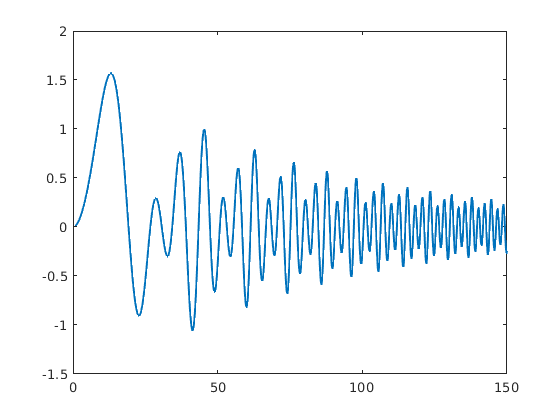

clf
plot(tspan, y_s,'LineWidth', 1.5)
hold on

%plot(tspan, y_1)
%plot(tspan, y_2)

% Perform ensemble EMD
Ne = 350;
sigma_e = 0.25; % still works with sigma = 1.5
rng(50);
[m,n] = size(y_s);

imf_eemd = eEMD(y_s, sigma_e, Ne, 10, 'pchip');

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030814   |  SiftMaxRelativeTolerance
      2      |        2     |     0.064138   |  SiftMaxRelativeTolerance
      3      |        2     |     0.069185   |  SiftMaxRelativeTolerance
      4      |        2     |     0.070732   |  SiftMaxRelativeTolerance
      5      |        2     |     0.086525   |  SiftMaxRelativeTolerance
      6      |        2     |        0.181   |  SiftMaxRelativeTolerance
      7      |        5     |      0.18287   |  SiftMaxRelativeTolerance
      8      |        3     |      0.11324   |  SiftMaxRelativeTolerance
      9      |        2     |      0.07084   |  SiftMaxRelativeTolerance
     10      |        2     |     0.019563   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.2162    0.2667   -0.0094   -0.0262   -0.0115    0.0060   -0.0080    0.0012   -0.0017   -0.6666
    0.3882   -0.1887   -0.0641   -0.0359   -0.0094    0.0056   -0.0079    0.0012   -0.0017   -0.6666
   -0.4072   -0.2371   -0.0957   -0.0446   -0.0074    0.0052   -0.0079    0.0012   -0.0017   -0.6666
    0.3299    0.0075   -0.0920   -0.0525   -0.0054    0.0048   -0.0078    0.0012   -0.0016   -0.6666
   -0.2530    0.2092   -0.0632   -0.0597   -0.0034    0.0043   -0.0077    0.0011   -0.0016   -0.6666
    0.1701    0.1346   -0.0220   -0.0664   -0.0014    0.0039   -0.0076    0.0011   -0.0016   -0.6666
    0.2586    0.0216    0.0169   -0.0722    0.0005    0.0034   -0.0075    0.0011   -0.0016   -0.6666
   -0.2303   -0.1282    0.0421   -0.0772    0.0024    0.0030   -0.0074    0.0011   -0.0016   -0.6666
    0.1669   -0.1324    0.0542   -0.0811    0.0042    0.0025   -0.0073    0.0011   -0.0015   -0.6666
   -0.1494   -0.0076    0.0632   -0.0839    0.0060    0.0020   -0.0072    0.0010   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031439   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062982   |  SiftMaxRelativeTolerance
      3      |        2     |     0.073803   |  SiftMaxRelativeTolerance
      4      |        2     |     0.074093   |  SiftMaxRelativeTolerance
      5      |        2     |     0.088601   |  SiftMaxRelativeTolerance
      6      |        3     |     0.044728   |  SiftMaxRelativeTolerance
      7      |        3     |     0.093815   |  SiftMaxRelativeTolerance
      8      |        2     |      0.18648   |  SiftMaxRelativeTolerance
      9      |        2     |     0.097245   |  SiftMaxRelativeTolerance
     10      |        2     |     0.019608   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0121   -0.0743   -0.0020   -0.0579    0.0354    0.0175   -0.0319   -0.0030    0.0006   -0.8194
    0.1983   -0.0767    0.0283   -0.0618    0.0379    0.0176   -0.0319   -0.0030    0.0006   -0.8194
   -0.0066   -0.0181    0.0585   -0.0654    0.0402    0.0177   -0.0319   -0.0029    0.0006   -0.8194
   -0.2673    0.0850    0.0836   -0.0688    0.0425    0.0178   -0.0320   -0.0029    0.0006   -0.8194
    0.2896    0.1217    0.0985   -0.0716    0.0445    0.0179   -0.0320   -0.0029    0.0006   -0.8194
    0.1840    0.0499    0.1036   -0.0739    0.0464    0.0180   -0.0320   -0.0028    0.0006   -0.8194
   -0.2401   -0.0575    0.1007   -0.0736    0.0479    0.0181   -0.0320   -0.0028    0.0006   -0.8194
    0.0215   -0.1185    0.0891   -0.0691    0.0492    0.0182   -0.0321   -0.0028    0.0006   -0.8194
    0.1531   -0.0828    0.0654   -0.0610    0.0501    0.0183   -0.0321   -0.0028    0.0006   -0.8194
    0.0372    0.0226    0.0293   -0.0499    0.0508    0.0184   -0.0321   -0.0027    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030439   |  SiftMaxRelativeTolerance
      2      |        2     |     0.061737   |  SiftMaxRelativeTolerance
      3      |        2     |     0.072071   |  SiftMaxRelativeTolerance
      4      |        2     |     0.076941   |  SiftMaxRelativeTolerance
      5      |        2     |     0.082439   |  SiftMaxRelativeTolerance
      6      |        2     |      0.16665   |  SiftMaxRelativeTolerance
      7      |        4     |     0.081198   |  SiftMaxRelativeTolerance
      8      |        3     |      0.19864   |  SiftMaxRelativeTolerance
      9      |        3     |     0.015776   |  SiftMaxRelativeTolerance
     10      |        2     |    0.0096092   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.2314    0.0162   -0.0079    0.0259    0.0064    0.0072   -0.0063   -0.0148    0.0070   -0.6081
   -0.1910   -0.0934   -0.0196    0.0235    0.0056    0.0077   -0.0063   -0.0147    0.0071   -0.6081
    0.1171   -0.0071   -0.0145    0.0196    0.0048    0.0082   -0.0064   -0.0147    0.0071   -0.6080
   -0.0382    0.0615    0.0071    0.0136    0.0040    0.0087   -0.0064   -0.0146    0.0071   -0.6080
    0.0349   -0.0092    0.0226    0.0063    0.0032    0.0093   -0.0065   -0.0145    0.0072   -0.6080
   -0.1270   -0.0253    0.0180   -0.0017    0.0024    0.0098   -0.0065   -0.0145    0.0072   -0.6079
   -0.1609    0.0124    0.0036   -0.0099    0.0015    0.0104   -0.0066   -0.0144    0.0073   -0.6079
    0.2042    0.0230   -0.0084   -0.0176    0.0007    0.0110   -0.0066   -0.0143    0.0073   -0.6079
   -0.2095   -0.0068   -0.0201   -0.0241   -0.0002    0.0115   -0.0067   -0.0143    0.0074   -0.6078
    0.0086   -0.0335   -0.0295   -0.0289   -0.0010    0.0121   -0.0067   -0.0142    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031452   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063103   |  SiftMaxRelativeTolerance
      3      |        2     |     0.068261   |  SiftMaxRelativeTolerance
      4      |        2     |     0.068827   |  SiftMaxRelativeTolerance
      5      |        2     |      0.08852   |  SiftMaxRelativeTolerance
      6      |        2     |      0.15766   |  SiftMaxRelativeTolerance
      7      |        6     |     0.012667   |  SiftMaxRelativeTolerance
      8      |        4     |       0.1099   |  SiftMaxRelativeTolerance
      9      |        2     |      0.15927   |  SiftMaxRelativeTolerance
     10      |        2     |      0.02974   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0178   -0.0344   -0.0409   -0.0647   -0.0367   -0.0345    0.0096   -0.0141   -0.0104   -0.5472
   -0.2519   -0.0775   -0.0311   -0.0596   -0.0311   -0.0325    0.0104   -0.0138   -0.0101   -0.5471
    0.1425   -0.1062   -0.0228   -0.0520   -0.0254   -0.0305    0.0112   -0.0135   -0.0098   -0.5470
    0.2473   -0.1160   -0.0124   -0.0423   -0.0197   -0.0285    0.0121   -0.0132   -0.0095   -0.5469
   -0.0253   -0.0640    0.0024   -0.0310   -0.0140   -0.0264    0.0129   -0.0129   -0.0093   -0.5468
   -0.2753    0.0319    0.0182   -0.0185   -0.0083   -0.0244    0.0138   -0.0126   -0.0090   -0.5466
    0.2620    0.1106    0.0316   -0.0054   -0.0028   -0.0223    0.0146   -0.0122   -0.0087   -0.5465
    0.2386    0.0899    0.0402    0.0079    0.0027   -0.0202    0.0155   -0.0119   -0.0084   -0.5464
   -0.1165   -0.0253    0.0430    0.0209    0.0080   -0.0181    0.0164   -0.0116   -0.0081   -0.5463
    0.0884   -0.1126    0.0381    0.0333    0.0131   -0.0160    0.0173   -0.0113   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030821   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062006   |  SiftMaxRelativeTolerance
      3      |        2     |     0.074672   |  SiftMaxRelativeTolerance
      4      |        2     |     0.074481   |  SiftMaxRelativeTolerance
      5      |        2     |     0.091859   |  SiftMaxRelativeTolerance
      6      |        2     |      0.19609   |  SiftMaxRelativeTolerance
      7      |        5     |      0.11543   |  SiftMaxRelativeTolerance
      8      |        3     |      0.10021   |  SiftMaxRelativeTolerance
      9      |        3     |      0.01057   |  SiftMaxRelativeTolerance
     10      |        2     |     0.014499   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.1341    0.0678    0.0424    0.0205    0.0131   -0.0118    0.0168   -0.0022    0.0037   -0.5351
   -0.2951   -0.0423    0.0064    0.0228    0.0132   -0.0119    0.0168   -0.0023    0.0037   -0.5351
   -0.0438   -0.0534   -0.0202    0.0254    0.0133   -0.0120    0.0169   -0.0023    0.0038   -0.5351
    0.1208    0.0178   -0.0362    0.0279    0.0134   -0.0120    0.0170   -0.0024    0.0038   -0.5351
   -0.0730    0.0546   -0.0464    0.0302    0.0135   -0.0121    0.0170   -0.0025    0.0038   -0.5351
    0.0827   -0.0196   -0.0494    0.0321    0.0136   -0.0122    0.0171   -0.0025    0.0038   -0.5350
   -0.1226   -0.0567   -0.0456    0.0336    0.0137   -0.0123    0.0172   -0.0026    0.0038   -0.5350
    0.1149   -0.0248   -0.0332    0.0346    0.0138   -0.0123    0.0172   -0.0027    0.0038   -0.5350
    0.2153   -0.0106   -0.0124    0.0351    0.0139   -0.0124    0.0173   -0.0027    0.0039   -0.5350
   -0.2335   -0.0067    0.0122    0.0351    0.0140   -0.0125    0.0174   -0.0028    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030148   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062098   |  SiftMaxRelativeTolerance
      3      |        2     |     0.074571   |  SiftMaxRelativeTolerance
      4      |        2     |     0.071405   |  SiftMaxRelativeTolerance
      5      |        2     |     0.085042   |  SiftMaxRelativeTolerance
      6      |        2     |      0.18424   |  SiftMaxRelativeTolerance
      7      |        4     |      0.11853   |  SiftMaxRelativeTolerance
      8      |        3     |      0.10415   |  SiftMaxRelativeTolerance
      9      |        1     |      0.13493   |  SiftMaxRelativeTolerance
     10      |        2     |     0.085895   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1607   -0.0011   -0.0008    0.0764   -0.0119   -0.0742   -0.0060   -0.0272   -0.5851    0.0722
   -0.1041    0.0385    0.0038    0.0700   -0.0090   -0.0725   -0.0059   -0.0272   -0.5851    0.0722
    0.1112    0.0797    0.0088    0.0634   -0.0060   -0.0707   -0.0058   -0.0273   -0.5850    0.0722
    0.1568    0.1066    0.0128    0.0567   -0.0031   -0.0689   -0.0057   -0.0273   -0.5850    0.0722
   -0.1038   -0.0013    0.0119    0.0492   -0.0002   -0.0670   -0.0056   -0.0274   -0.5850    0.0722
    0.0445   -0.0991    0.0050    0.0408    0.0027   -0.0652   -0.0055   -0.0274   -0.5849    0.0722
   -0.0467   -0.0413   -0.0031    0.0316    0.0055   -0.0633   -0.0054   -0.0274   -0.5849    0.0722
    0.0091    0.0293   -0.0082    0.0219    0.0083   -0.0614   -0.0053   -0.0275   -0.5849    0.0722
    0.1370    0.0746   -0.0075    0.0120    0.0110   -0.0594   -0.0052   -0.0275   -0.5849    0.0722
    0.1739    0.0675   -0.0029    0.0020    0.0136   -0.0575   -0.0051   -0.0276   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030792   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062119   |  SiftMaxRelativeTolerance
      3      |        2     |     0.068284   |  SiftMaxRelativeTolerance
      4      |        2     |       0.0765   |  SiftMaxRelativeTolerance
      5      |        2     |       0.0729   |  SiftMaxRelativeTolerance
      6      |        3     |     0.051504   |  SiftMaxRelativeTolerance
      7      |        4     |     0.038162   |  SiftMaxRelativeTolerance
      8      |        3     |      0.17866   |  SiftMaxRelativeTolerance
      9      |        3     |     0.018937   |  SiftMaxRelativeTolerance
     10      |        1     |      0.18629   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1330    0.1098    0.0921    0.0244    0.0051    0.0595    0.0182    0.0030    0.0002   -0.6802
    0.1917   -0.0697    0.0133    0.0057    0.0029    0.0596    0.0179    0.0028    0.0002   -0.6802
   -0.2411   -0.0450   -0.0726   -0.0122    0.0005    0.0597    0.0176    0.0025    0.0002   -0.6802
   -0.1198    0.0038   -0.1537   -0.0287   -0.0019    0.0597    0.0172    0.0023    0.0002   -0.6801
    0.3548    0.0171   -0.2108   -0.0433   -0.0045    0.0596    0.0169    0.0020    0.0002   -0.6801
   -0.3276   -0.0428   -0.2072   -0.0556   -0.0070    0.0596    0.0166    0.0018    0.0002   -0.6800
    0.1454    0.0433   -0.1490   -0.0637   -0.0096    0.0595    0.0163    0.0016    0.0002   -0.6800
   -0.0065    0.1894   -0.0819   -0.0666   -0.0121    0.0593    0.0159    0.0013    0.0002   -0.6800
    0.0352    0.1807   -0.0389   -0.0649   -0.0146    0.0592    0.0156    0.0011    0.0002   -0.6799
    0.1425    0.1318   -0.0162   -0.0592   -0.0171    0.0590    0.0153    0.0008    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030296   |  SiftMaxRelativeTolerance
      2      |        2     |     0.060711   |  SiftMaxRelativeTolerance
      3      |        2     |      0.07326   |  SiftMaxRelativeTolerance
      4      |        2     |     0.073529   |  SiftMaxRelativeTolerance
      5      |        2     |     0.096354   |  SiftMaxRelativeTolerance
      6      |        3     |     0.059298   |  SiftMaxRelativeTolerance
      7      |        3     |      0.12655   |  SiftMaxRelativeTolerance
      8      |        3     |     0.040073   |  SiftMaxRelativeTolerance
      9      |        3     |     0.028659   |  SiftMaxRelativeTolerance
     10      |        1     |      0.16787   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.4957    0.0868    0.0098   -0.0347   -0.0184   -0.0258   -0.0124   -0.0203   -0.0008   -0.6788
   -0.0700   -0.0767   -0.0001   -0.0415   -0.0160   -0.0224   -0.0117   -0.0196   -0.0004   -0.6787
   -0.4180   -0.2017   -0.0094   -0.0484   -0.0137   -0.0190   -0.0109   -0.0190   -0.0001   -0.6786
    0.1770   -0.2289   -0.0171   -0.0553   -0.0113   -0.0154   -0.0102   -0.0183    0.0002   -0.6785
    0.3155   -0.1615   -0.0204   -0.0622   -0.0090   -0.0118   -0.0094   -0.0176    0.0006   -0.6784
    0.2335   -0.0378   -0.0179   -0.0691   -0.0068   -0.0080   -0.0087   -0.0169    0.0009   -0.6783
    0.0124    0.1002   -0.0109   -0.0759   -0.0046   -0.0042   -0.0079   -0.0162    0.0012   -0.6782
   -0.1531    0.1782   -0.0008   -0.0825   -0.0024   -0.0004   -0.0071   -0.0154    0.0016   -0.6781
    0.1523    0.1784    0.0112   -0.0888   -0.0003    0.0035   -0.0063   -0.0146    0.0019   -0.6780
   -0.0761    0.1507    0.0207   -0.0948    0.0017    0.0074   -0.0055   -0.0138    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031905   |  SiftMaxRelativeTolerance
      2      |        2     |      0.06347   |  SiftMaxRelativeTolerance
      3      |        2     |     0.068467   |  SiftMaxRelativeTolerance
      4      |        2     |     0.069661   |  SiftMaxRelativeTolerance
      5      |        2     |     0.081397   |  SiftMaxRelativeTolerance
      6      |        2     |      0.18032   |  SiftMaxRelativeTolerance
      7      |        5     |     0.017573   |  SiftMaxRelativeTolerance
      8      |        3     |       0.1163   |  SiftMaxRelativeTolerance
      9      |        3     |     0.041279   |  SiftMaxRelativeTolerance
     10      |        2     |     0.055565   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0528    0.0295    0.0151   -0.0336    0.0846    0.0409    0.0053    0.0123   -0.0005   -0.8894
    0.0668   -0.0200   -0.0069   -0.0300    0.0741    0.0366    0.0048    0.0120   -0.0006   -0.8894
   -0.0938    0.0005   -0.0297   -0.0275    0.0630    0.0322    0.0044    0.0117   -0.0007   -0.8894
   -0.0206    0.0153   -0.0484   -0.0250    0.0515    0.0277    0.0040    0.0114   -0.0008   -0.8894
    0.1878   -0.0135   -0.0469   -0.0223    0.0396    0.0231    0.0035    0.0111   -0.0010   -0.8894
   -0.1708   -0.0726   -0.0204   -0.0207    0.0276    0.0185    0.0031    0.0108   -0.0011   -0.8894
    0.0752   -0.0187    0.0174   -0.0214    0.0154    0.0139    0.0027    0.0105   -0.0012   -0.8894
   -0.0337    0.1169    0.0493   -0.0238    0.0032    0.0093    0.0023    0.0101   -0.0013   -0.8895
    0.0961    0.1693    0.0619   -0.0280   -0.0089    0.0046    0.0019    0.0098   -0.0014   -0.8895
   -0.1544    0.1573    0.0574   -0.0338   -0.0208    0.0000    0.0015    0.0095   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.03098   |  SiftMaxRelativeTolerance
      2      |        2     |     0.061701   |  SiftMaxRelativeTolerance
      3      |        2     |     0.068291   |  SiftMaxRelativeTolerance
      4      |        2     |     0.073633   |  SiftMaxRelativeTolerance
      5      |        2     |     0.093522   |  SiftMaxRelativeTolerance
      6      |        3     |     0.035968   |  SiftMaxRelativeTolerance
      7      |        5     |     0.075186   |  SiftMaxRelativeTolerance
      8      |        3     |      0.18804   |  SiftMaxRelativeTolerance
      9      |        1     |       0.1384   |  SiftMaxRelativeTolerance
     10      |        3     |       0.0219   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0091   -0.0340   -0.0852   -0.0247   -0.0577   -0.0434   -0.0300   -0.0084   -0.6899   -0.0473
   -0.0347    0.0565   -0.0425   -0.0167   -0.0554   -0.0417   -0.0292   -0.0083   -0.6897   -0.0474
    0.0915    0.0691    0.0107   -0.0076   -0.0529   -0.0399   -0.0285   -0.0081   -0.6896   -0.0474
   -0.1703    0.0579    0.0647    0.0021   -0.0502   -0.0381   -0.0277   -0.0079   -0.6895   -0.0474
    0.2127    0.0083    0.1085    0.0120   -0.0472   -0.0362   -0.0269   -0.0077   -0.6893   -0.0474
   -0.2147   -0.0880    0.1365    0.0214   -0.0440   -0.0343   -0.0262   -0.0076   -0.6892   -0.0474
    0.1943   -0.0803    0.1419    0.0300   -0.0407   -0.0323   -0.0254   -0.0074   -0.6890   -0.0474
   -0.2119    0.0424    0.1201    0.0379   -0.0372   -0.0302   -0.0247   -0.0072   -0.6889   -0.0474
    0.1487    0.1428    0.0722    0.0455   -0.0335   -0.0281   -0.0239   -0.0070   -0.6887   -0.0474
    0.3521    0.1471    0.0106    0.0526   -0.0297   -0.0260   -0.0232   -0.0069   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031181   |  SiftMaxRelativeTolerance
      2      |        2     |     0.061861   |  SiftMaxRelativeTolerance
      3      |        2     |     0.068307   |  SiftMaxRelativeTolerance
      4      |        2     |     0.076485   |  SiftMaxRelativeTolerance
      5      |        2     |     0.075852   |  SiftMaxRelativeTolerance
      6      |        3     |     0.048802   |  SiftMaxRelativeTolerance
      7      |        3     |      0.13626   |  SiftMaxRelativeTolerance
      8      |        2     |      0.17615   |  SiftMaxRelativeTolerance
      9      |        3     |     0.051893   |  SiftMaxRelativeTolerance
     10      |        2     |     0.042073   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.3530   -0.0417    0.0855   -0.0716    0.0046   -0.0271   -0.0069   -0.0112   -0.0203   -0.4207
   -0.3620    0.0552    0.0193   -0.0644    0.0043   -0.0271   -0.0068   -0.0112   -0.0203   -0.4207
    0.3352    0.1412   -0.0396   -0.0564    0.0039   -0.0271   -0.0066   -0.0113   -0.0203   -0.4207
   -0.1317    0.1215   -0.0861   -0.0478    0.0035   -0.0271   -0.0065   -0.0113   -0.0203   -0.4207
   -0.1869   -0.0160   -0.1213   -0.0388    0.0030   -0.0270   -0.0064   -0.0114   -0.0203   -0.4207
    0.1825   -0.1654   -0.1368   -0.0299    0.0026   -0.0270   -0.0062   -0.0114   -0.0203   -0.4207
   -0.2135   -0.1343   -0.1228   -0.0197    0.0021   -0.0270   -0.0061   -0.0115   -0.0203   -0.4207
   -0.3814    0.0417   -0.0823   -0.0071    0.0016   -0.0270   -0.0060   -0.0115   -0.0203   -0.4207
    0.4250    0.1260   -0.0269    0.0070    0.0011   -0.0270   -0.0058   -0.0116   -0.0203   -0.4207
    0.1725    0.0738    0.0299    0.0221    0.0005   -0.0269   -0.0057   -0.0116   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030291   |  SiftMaxRelativeTolerance
      2      |        2     |      0.05957   |  SiftMaxRelativeTolerance
      3      |        2     |     0.066159   |  SiftMaxRelativeTolerance
      4      |        2     |     0.072469   |  SiftMaxRelativeTolerance
      5      |        2     |     0.090286   |  SiftMaxRelativeTolerance
      6      |        2     |      0.19783   |  SiftMaxRelativeTolerance
      7      |        5     |      0.10824   |  SiftMaxRelativeTolerance
      8      |        2     |      0.11474   |  SiftMaxRelativeTolerance
      9      |        2     |     0.034703   |  SiftMaxRelativeTolerance
     10      |        2     |     0.045674   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.2213    0.0561    0.0639   -0.0736   -0.0041    0.0601    0.0190    0.0110    0.0282   -0.3431
    0.2344   -0.0097    0.0356   -0.0701   -0.0055    0.0592    0.0183    0.0108    0.0281   -0.3430
   -0.2245   -0.0386    0.0012   -0.0665   -0.0069    0.0582    0.0177    0.0105    0.0279   -0.3430
   -0.0513   -0.0515   -0.0330   -0.0626   -0.0082    0.0571    0.0170    0.0103    0.0277   -0.3430
    0.1459   -0.0569   -0.0605   -0.0586   -0.0096    0.0559    0.0163    0.0101    0.0276   -0.3430
    0.1730   -0.0522   -0.0733   -0.0544   -0.0108    0.0545    0.0156    0.0099    0.0274   -0.3430
   -0.1621   -0.0329   -0.0643   -0.0499   -0.0121    0.0531    0.0149    0.0097    0.0272   -0.3430
    0.1421    0.0205   -0.0402   -0.0451   -0.0133    0.0515    0.0142    0.0095    0.0271   -0.3430
   -0.1183    0.0358   -0.0131   -0.0399   -0.0144    0.0498    0.0135    0.0092    0.0269   -0.3430
    0.1240   -0.0269    0.0180   -0.0345   -0.0155    0.0481    0.0128    0.0090    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031409   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062284   |  SiftMaxRelativeTolerance
      3      |        2     |     0.066603   |  SiftMaxRelativeTolerance
      4      |        2     |     0.071025   |  SiftMaxRelativeTolerance
      5      |        2     |      0.10236   |  SiftMaxRelativeTolerance
      6      |        3     |     0.039142   |  SiftMaxRelativeTolerance
      7      |        4     |     0.044128   |  SiftMaxRelativeTolerance
      8      |        2     |      0.10352   |  SiftMaxRelativeTolerance
      9      |        1     |      0.11495   |  SiftMaxRelativeTolerance
     10      |        2     |     0.016484   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1457    0.0512    0.0413   -0.0421   -0.0131   -0.0020   -0.0140   -0.0085   -0.0046   -0.2966
   -0.2334    0.0636    0.0458   -0.0524   -0.0141   -0.0022   -0.0140   -0.0084   -0.0045   -0.2966
   -0.1766    0.0512    0.0415   -0.0635   -0.0152   -0.0024   -0.0140   -0.0083   -0.0044   -0.2966
    0.2102    0.0092    0.0244   -0.0750   -0.0162   -0.0025   -0.0140   -0.0082   -0.0043   -0.2966
    0.3164   -0.0353    0.0010   -0.0861   -0.0171   -0.0027   -0.0140   -0.0081   -0.0043   -0.2966
   -0.3618   -0.0301   -0.0221   -0.0956   -0.0181   -0.0030   -0.0139   -0.0080   -0.0042   -0.2966
   -0.1120    0.0062   -0.0333   -0.1026   -0.0190   -0.0032   -0.0139   -0.0079   -0.0041   -0.2966
    0.4492    0.0086   -0.0275   -0.1065   -0.0198   -0.0034   -0.0138   -0.0078   -0.0040   -0.2966
   -0.4576   -0.0102   -0.0082   -0.1074   -0.0206   -0.0037   -0.0138   -0.0077   -0.0039   -0.2966
    0.0378    0.0018    0.0106   -0.1056   -0.0213   -0.0039   -0.0137   -0.0075   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031414   |  SiftMaxRelativeTolerance
      2      |        2     |     0.060095   |  SiftMaxRelativeTolerance
      3      |        2     |     0.067389   |  SiftMaxRelativeTolerance
      4      |        2     |     0.075026   |  SiftMaxRelativeTolerance
      5      |        2     |     0.094976   |  SiftMaxRelativeTolerance
      6      |        2     |      0.19749   |  SiftMaxRelativeTolerance
      7      |        4     |     0.047871   |  SiftMaxRelativeTolerance
      8      |        3     |     0.048432   |  SiftMaxRelativeTolerance
      9      |        1     |      0.13194   |  SiftMaxRelativeTolerance
     10      |        2     |     0.065288   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0911   -0.0189   -0.0957   -0.1244   -0.0676   -0.0378   -0.0168   -0.0156   -0.6715    0.1005
   -0.1127    0.0416   -0.0870   -0.1044   -0.0578   -0.0360   -0.0162   -0.0154   -0.6714    0.1004
    0.1385    0.0149   -0.0730   -0.0828   -0.0478   -0.0342   -0.0157   -0.0152   -0.6713    0.1004
   -0.0829   -0.0319   -0.0546   -0.0601   -0.0378   -0.0323   -0.0151   -0.0150   -0.6711    0.1004
   -0.2014   -0.0585   -0.0351   -0.0369   -0.0279   -0.0305   -0.0146   -0.0147   -0.6710    0.1004
   -0.0412   -0.0504   -0.0156   -0.0135   -0.0179   -0.0286   -0.0140   -0.0145   -0.6709    0.1004
    0.0346   -0.0216    0.0039    0.0095   -0.0081   -0.0267   -0.0135   -0.0143   -0.6708    0.1004
    0.2363    0.0147    0.0219    0.0317    0.0015   -0.0248   -0.0129   -0.0141   -0.6707    0.1004
    0.1358    0.0537    0.0364    0.0525    0.0109   -0.0229   -0.0123   -0.0139   -0.6705    0.1004
   -0.0005    0.0914    0.0457    0.0715    0.0199   -0.0210   -0.0117   -0.0137   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030488   |  SiftMaxRelativeTolerance
      2      |        2     |     0.061108   |  SiftMaxRelativeTolerance
      3      |        2     |     0.072384   |  SiftMaxRelativeTolerance
      4      |        2     |     0.069657   |  SiftMaxRelativeTolerance
      5      |        2     |     0.084206   |  SiftMaxRelativeTolerance
      6      |        2     |       0.1922   |  SiftMaxRelativeTolerance
      7      |        5     |     0.056041   |  SiftMaxRelativeTolerance
      8      |        4     |       0.1422   |  SiftMaxRelativeTolerance
      9      |        1     |      0.13153   |  SiftMaxRelativeTolerance
     10      |        2     |     0.038025   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.3984   -0.0161   -0.1048    0.0177    0.0178    0.0800    0.0071    0.0080    0.0148   -0.2681
    0.1284   -0.1790   -0.1167    0.0144    0.0177    0.0760    0.0065    0.0078    0.0145   -0.2681
   -0.2834   -0.2708   -0.1259    0.0113    0.0172    0.0720    0.0058    0.0075    0.0143   -0.2682
   -0.1663   -0.2620   -0.1322    0.0083    0.0163    0.0678    0.0051    0.0072    0.0140   -0.2682
    0.2249   -0.1972   -0.1367    0.0054    0.0152    0.0635    0.0044    0.0070    0.0138   -0.2682
   -0.2166   -0.0971   -0.1404    0.0027    0.0138    0.0591    0.0037    0.0067    0.0135   -0.2682
    0.0073    0.0128   -0.1432    0.0001    0.0122    0.0547    0.0029    0.0065    0.0132   -0.2683
    0.2441    0.0979   -0.1448   -0.0023    0.0104    0.0502    0.0021    0.0062    0.0130   -0.2683
   -0.0969    0.1449   -0.1453   -0.0044    0.0084    0.0455    0.0013    0.0060    0.0127   -0.2683
   -0.2648    0.1740   -0.1443   -0.0064    0.0063    0.0409    0.0005    0.0057    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031068   |  SiftMaxRelativeTolerance
      2      |        2     |     0.059151   |  SiftMaxRelativeTolerance
      3      |        2     |     0.072705   |  SiftMaxRelativeTolerance
      4      |        2     |      0.07793   |  SiftMaxRelativeTolerance
      5      |        2     |      0.08562   |  SiftMaxRelativeTolerance
      6      |        2     |      0.18529   |  SiftMaxRelativeTolerance
      7      |        5     |     0.037193   |  SiftMaxRelativeTolerance
      8      |        4     |     0.076046   |  SiftMaxRelativeTolerance
      9      |        3     |    0.0081931   |  SiftMaxRelativeTolerance
     10      |        1     |      0.18156   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.2919   -0.1485   -0.0557   -0.1525   -0.0576   -0.0043   -0.0044   -0.0088   -0.0085   -0.7047
   -0.1109    0.0225    0.0187   -0.1330   -0.0516   -0.0047   -0.0042   -0.0084   -0.0084   -0.7046
   -0.4033    0.1267    0.0934   -0.1126   -0.0456   -0.0051   -0.0039   -0.0080   -0.0082   -0.7046
   -0.1881    0.1864    0.1517   -0.0916   -0.0395   -0.0055   -0.0037   -0.0076   -0.0081   -0.7045
    0.2846    0.2431    0.1770   -0.0708   -0.0335   -0.0059   -0.0034   -0.0072   -0.0079   -0.7044
   -0.1324    0.1226    0.1713   -0.0507   -0.0275   -0.0063   -0.0031   -0.0068   -0.0078   -0.7043
    0.0613   -0.0981    0.1498   -0.0316   -0.0215   -0.0067   -0.0028   -0.0064   -0.0077   -0.7042
   -0.1116   -0.1896    0.1147   -0.0128   -0.0156   -0.0071   -0.0025   -0.0060   -0.0075   -0.7042
   -0.0518   -0.1515    0.0724    0.0061   -0.0097   -0.0075   -0.0022   -0.0056   -0.0074   -0.7041
    0.0535   -0.0326    0.0307    0.0247   -0.0039   -0.0079   -0.0019   -0.0052   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031079   |  SiftMaxRelativeTolerance
      2      |        2     |      0.06167   |  SiftMaxRelativeTolerance
      3      |        2     |     0.067428   |  SiftMaxRelativeTolerance
      4      |        2     |     0.072064   |  SiftMaxRelativeTolerance
      5      |        2     |     0.087409   |  SiftMaxRelativeTolerance
      6      |        2     |      0.19863   |  SiftMaxRelativeTolerance
      7      |        3     |       0.1801   |  SiftMaxRelativeTolerance
      8      |        2     |      0.19665   |  SiftMaxRelativeTolerance
      9      |        1     |      0.17496   |  SiftMaxRelativeTolerance
     10      |        2     |     0.056241   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0665    0.0196   -0.0383   -0.0048   -0.0060   -0.0107   -0.0115    0.0060   -0.6813    0.1054
    0.2607    0.0666   -0.0414    0.0073   -0.0040   -0.0105   -0.0114    0.0060   -0.6812    0.1054
    0.1597    0.0344   -0.0369    0.0214   -0.0021   -0.0103   -0.0113    0.0060   -0.6811    0.1053
   -0.1332   -0.0570   -0.0218    0.0361   -0.0002   -0.0100   -0.0111    0.0060   -0.6810    0.1053
    0.0809   -0.0721    0.0001    0.0505    0.0016   -0.0098   -0.0110    0.0060   -0.6808    0.1053
   -0.0851    0.0229    0.0248    0.0636    0.0034   -0.0095   -0.0109    0.0059   -0.6807    0.1053
    0.1047    0.0669    0.0429    0.0744    0.0051   -0.0092   -0.0108    0.0059   -0.6806    0.1053
    0.0097    0.0263    0.0492    0.0819    0.0067   -0.0090   -0.0107    0.0059   -0.6805    0.1053
   -0.0940   -0.0205    0.0471    0.0851    0.0082   -0.0087   -0.0105    0.0059   -0.6804    0.1053
    0.0922   -0.0408    0.0356    0.0855    0.0096   -0.0084   -0.0104    0.0059   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.03125   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063043   |  SiftMaxRelativeTolerance
      3      |        2     |       0.0703   |  SiftMaxRelativeTolerance
      4      |        2     |     0.076709   |  SiftMaxRelativeTolerance
      5      |        2     |     0.094868   |  SiftMaxRelativeTolerance
      6      |        2     |      0.16665   |  SiftMaxRelativeTolerance
      7      |        6     |     0.040551   |  SiftMaxRelativeTolerance
      8      |        5     |       0.1254   |  SiftMaxRelativeTolerance
      9      |        2     |     0.093127   |  SiftMaxRelativeTolerance
     10      |        3     |       0.1227   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0230   -0.0322   -0.0325   -0.0954   -0.0202   -0.0046   -0.0244    0.0011   -0.0101    0.0024
    0.2898   -0.0001   -0.0183   -0.0838   -0.0147   -0.0039   -0.0244    0.0011   -0.0101    0.0024
    0.0036    0.0315   -0.0008   -0.0688   -0.0091   -0.0033   -0.0244    0.0012   -0.0101    0.0024
   -0.2887    0.0550    0.0167   -0.0515   -0.0036   -0.0027   -0.0244    0.0013   -0.0100    0.0024
    0.1854    0.0594    0.0306   -0.0329    0.0020   -0.0020   -0.0244    0.0014   -0.0100    0.0024
    0.2919    0.0471    0.0375   -0.0140    0.0075   -0.0014   -0.0243    0.0014   -0.0099    0.0024
   -0.2454    0.0016    0.0359    0.0043    0.0129   -0.0008   -0.0243    0.0015   -0.0099    0.0024
   -0.2337   -0.0617    0.0263    0.0211    0.0183   -0.0002   -0.0243    0.0016   -0.0099    0.0025
    0.1516    0.0055    0.0080    0.0354    0.0237    0.0004   -0.0243    0.0017   -0.0098    0.0025
   -0.0813    0.0800   -0.0161    0.0477    0.0289    0.0010   -0.0243    0.0017   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.03048   |  SiftMaxRelativeTolerance
      2      |        2     |     0.061778   |  SiftMaxRelativeTolerance
      3      |        2     |     0.069439   |  SiftMaxRelativeTolerance
      4      |        2     |     0.072309   |  SiftMaxRelativeTolerance
      5      |        2     |      0.08766   |  SiftMaxRelativeTolerance
      6      |        2     |      0.18135   |  SiftMaxRelativeTolerance
      7      |        7     |     0.021247   |  SiftMaxRelativeTolerance
      8      |        3     |      0.10847   |  SiftMaxRelativeTolerance
      9      |        4     |     0.031719   |  SiftMaxRelativeTolerance
     10      |        2     |     0.032431   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1861   -0.1504    0.1143    0.1594    0.0207    0.0774   -0.0007    0.0195    0.0126   -0.8723
   -0.2321   -0.1892    0.0437    0.1439    0.0179    0.0768   -0.0012    0.0189    0.0124   -0.8723
   -0.2471   -0.2181   -0.0288    0.1273    0.0151    0.0761   -0.0018    0.0184    0.0121   -0.8724
    0.2083   -0.2127   -0.0980    0.1100    0.0122    0.0755   -0.0023    0.0178    0.0119   -0.8724
    0.1089   -0.2219   -0.1587    0.0923    0.0095    0.0747   -0.0029    0.0172    0.0117   -0.8724
   -0.0971   -0.2567   -0.2058    0.0742    0.0067    0.0739   -0.0034    0.0167    0.0115   -0.8724
    0.0831   -0.2512   -0.2341    0.0562    0.0040    0.0731   -0.0039    0.0161    0.0113   -0.8725
   -0.0994   -0.1090   -0.2469    0.0385    0.0014    0.0722   -0.0045    0.0155    0.0110   -0.8725
    0.1105    0.1086   -0.2495    0.0212   -0.0012    0.0713   -0.0050    0.0150    0.0108   -0.8725
   -0.1075    0.2225   -0.2393    0.0044   -0.0037    0.0704   -0.0055    0.0144    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031429   |  SiftMaxRelativeTolerance
      2      |        2     |     0.061919   |  SiftMaxRelativeTolerance
      3      |        2     |     0.070544   |  SiftMaxRelativeTolerance
      4      |        2     |     0.075326   |  SiftMaxRelativeTolerance
      5      |        2     |     0.088344   |  SiftMaxRelativeTolerance
      6      |        3     |     0.042109   |  SiftMaxRelativeTolerance
      7      |        4     |     0.039706   |  SiftMaxRelativeTolerance
      8      |        2     |      0.14978   |  SiftMaxRelativeTolerance
      9      |        5     |     0.013215   |  SiftMaxRelativeTolerance
     10      |        2     |     0.028909   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.2604   -0.0243    0.1154    0.0984    0.0180    0.0109    0.0135    0.0065    0.0078   -0.8686
    0.3111   -0.1393    0.0988    0.0861    0.0146    0.0104    0.0134    0.0062    0.0077   -0.8686
   -0.3223   -0.1235    0.0804    0.0723    0.0112    0.0099    0.0132    0.0060    0.0076   -0.8686
    0.0520   -0.0593    0.0566    0.0572    0.0078    0.0094    0.0131    0.0058    0.0075   -0.8687
    0.1645    0.0222    0.0261    0.0411    0.0045    0.0088    0.0129    0.0056    0.0074   -0.8687
    0.3151    0.1035   -0.0064    0.0242    0.0011    0.0083    0.0127    0.0054    0.0073   -0.8687
    0.0692    0.1434   -0.0391    0.0069   -0.0022    0.0078    0.0125    0.0052    0.0072   -0.8688
   -0.2449    0.1388   -0.0721   -0.0106   -0.0055    0.0073    0.0123    0.0050    0.0070   -0.8688
    0.1990    0.1414   -0.1028   -0.0279   -0.0087    0.0068    0.0121    0.0048    0.0069   -0.8689
   -0.1759    0.1051   -0.1275   -0.0450   -0.0120    0.0063    0.0118    0.0046    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031401   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062027   |  SiftMaxRelativeTolerance
      3      |        2     |     0.064611   |  SiftMaxRelativeTolerance
      4      |        2     |     0.077916   |  SiftMaxRelativeTolerance
      5      |        2     |     0.082503   |  SiftMaxRelativeTolerance
      6      |        2     |      0.18605   |  SiftMaxRelativeTolerance
      7      |        5     |     0.027629   |  SiftMaxRelativeTolerance
      8      |        2     |      0.18857   |  SiftMaxRelativeTolerance
      9      |        2     |      0.11834   |  SiftMaxRelativeTolerance
     10      |        2     |     0.014556   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0684    0.0099   -0.0486   -0.0055   -0.0334    0.0276    0.0046   -0.0031   -0.0095   -0.7190
   -0.2073    0.0465   -0.0269    0.0001   -0.0280    0.0255    0.0050   -0.0029   -0.0094   -0.7189
    0.1034    0.0234   -0.0031    0.0048   -0.0223    0.0235    0.0056   -0.0026   -0.0093   -0.7189
    0.3108   -0.0396    0.0185    0.0083   -0.0163    0.0213    0.0061   -0.0023   -0.0092   -0.7189
   -0.3459   -0.0603    0.0347    0.0100   -0.0102    0.0191    0.0067   -0.0021   -0.0091   -0.7189
   -0.0770    0.0010    0.0395    0.0095   -0.0043    0.0169    0.0072   -0.0018   -0.0090   -0.7188
    0.3158    0.0887    0.0275    0.0075    0.0014    0.0147    0.0078   -0.0016   -0.0090   -0.7188
    0.1597    0.0819    0.0051    0.0051    0.0068    0.0124    0.0085   -0.0013   -0.0089   -0.7188
   -0.1825   -0.0310   -0.0158    0.0026    0.0116    0.0101    0.0091   -0.0010   -0.0088   -0.7188
    0.1644   -0.1340   -0.0298    0.0001    0.0156    0.0079    0.0098   -0.0008   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031028   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063706   |  SiftMaxRelativeTolerance
      3      |        2     |     0.070901   |  SiftMaxRelativeTolerance
      4      |        2     |     0.070115   |  SiftMaxRelativeTolerance
      5      |        2     |     0.094416   |  SiftMaxRelativeTolerance
      6      |        3     |     0.049335   |  SiftMaxRelativeTolerance
      7      |        5     |     0.077694   |  SiftMaxRelativeTolerance
      8      |        3     |     0.098447   |  SiftMaxRelativeTolerance
      9      |        2     |     0.049832   |  SiftMaxRelativeTolerance
     10      |        2     |      0.01905   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.5288   -0.0658    0.0439   -0.0159    0.0180    0.0059    0.0249   -0.0158    0.0112   -0.4109
   -0.0836   -0.0210    0.0453   -0.0194    0.0173    0.0064    0.0248   -0.0159    0.0112   -0.4109
    0.0050    0.0281    0.0465   -0.0228    0.0164    0.0068    0.0247   -0.0160    0.0112   -0.4109
    0.5292    0.0646    0.0477   -0.0261    0.0153    0.0073    0.0246   -0.0160    0.0112   -0.4109
   -0.4957    0.0323    0.0485   -0.0292    0.0140    0.0077    0.0245   -0.0161    0.0112   -0.4109
   -0.0206   -0.0359    0.0488   -0.0322    0.0126    0.0082    0.0245   -0.0162    0.0112   -0.4108
    0.1822   -0.0670    0.0487   -0.0349    0.0110    0.0086    0.0244   -0.0162    0.0112   -0.4108
    0.2315   -0.0292    0.0438   -0.0375    0.0092    0.0090    0.0243   -0.0163    0.0112   -0.4108
   -0.2220    0.0560    0.0315   -0.0399    0.0074    0.0095    0.0242   -0.0163    0.0112   -0.4108
    0.2348    0.0803    0.0151   -0.0420    0.0054    0.0099    0.0241   -0.0164    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.03099   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063149   |  SiftMaxRelativeTolerance
      3      |        2     |     0.070365   |  SiftMaxRelativeTolerance
      4      |        2     |     0.075793   |  SiftMaxRelativeTolerance
      5      |        2     |      0.08388   |  SiftMaxRelativeTolerance
      6      |        2     |      0.19643   |  SiftMaxRelativeTolerance
      7      |        5     |     0.082969   |  SiftMaxRelativeTolerance
      8      |        2     |      0.17512   |  SiftMaxRelativeTolerance
      9      |        3     |     0.016118   |  SiftMaxRelativeTolerance
     10      |        2     |     0.025028   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0460    0.0004   -0.1100    0.0083    0.0012   -0.0034    0.0076   -0.0024   -0.0329   -0.4115
   -0.1947    0.0652   -0.1111    0.0154    0.0012   -0.0032    0.0075   -0.0023   -0.0329   -0.4115
   -0.1536    0.1094   -0.1105    0.0226    0.0012   -0.0030    0.0073   -0.0022   -0.0329   -0.4115
    0.2066    0.1263   -0.1092    0.0298    0.0012   -0.0028    0.0072   -0.0021   -0.0329   -0.4115
   -0.1549   -0.0087   -0.1034    0.0367    0.0011   -0.0026    0.0071   -0.0020   -0.0330   -0.4115
    0.0982   -0.1328   -0.0911    0.0432    0.0011   -0.0024    0.0069   -0.0019   -0.0330   -0.4115
   -0.1125   -0.0448   -0.0524    0.0490    0.0011   -0.0022    0.0068   -0.0017   -0.0330   -0.4115
    0.1370    0.0420    0.0144    0.0538    0.0011   -0.0020    0.0067   -0.0016   -0.0330   -0.4115
   -0.1380    0.0235    0.0789    0.0576    0.0010   -0.0018    0.0065   -0.0015   -0.0331   -0.4115
    0.0090   -0.0009    0.1128    0.0599    0.0010   -0.0016    0.0064   -0.0014   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030323   |  SiftMaxRelativeTolerance
      2      |        2     |     0.061433   |  SiftMaxRelativeTolerance
      3      |        2     |     0.068007   |  SiftMaxRelativeTolerance
      4      |        2     |     0.073319   |  SiftMaxRelativeTolerance
      5      |        2     |     0.086885   |  SiftMaxRelativeTolerance
      6      |        3     |     0.049225   |  SiftMaxRelativeTolerance
      7      |        4     |     0.039782   |  SiftMaxRelativeTolerance
      8      |        3     |      0.12065   |  SiftMaxRelativeTolerance
      9      |        3     |    0.0086084   |  SiftMaxRelativeTolerance
     10      |        1     |      0.14729   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0222   -0.0084   -0.0201    0.0115   -0.0225    0.0299    0.0299    0.0022   -0.0148   -0.5510
   -0.0282   -0.0115   -0.0313    0.0124   -0.0229    0.0299    0.0300    0.0021   -0.0148   -0.5510
    0.0614   -0.0788   -0.0415    0.0132   -0.0233    0.0300    0.0300    0.0020   -0.0148   -0.5510
    0.0464   -0.1551   -0.0506    0.0140   -0.0237    0.0300    0.0301    0.0020   -0.0148   -0.5510
   -0.2179   -0.1355   -0.0567    0.0147   -0.0241    0.0301    0.0301    0.0019   -0.0148   -0.5510
   -0.2173   -0.0557   -0.0587    0.0154   -0.0244    0.0302    0.0301    0.0018   -0.0148   -0.5509
    0.3034   -0.0182   -0.0569    0.0157   -0.0247    0.0302    0.0302    0.0017   -0.0148   -0.5509
    0.1398   -0.0167   -0.0515    0.0153   -0.0249    0.0303    0.0302    0.0016   -0.0148   -0.5509
    0.1230   -0.0163   -0.0432    0.0142   -0.0248    0.0303    0.0303    0.0016   -0.0148   -0.5509
   -0.3139   -0.0167   -0.0326    0.0124   -0.0244    0.0303    0.0303    0.0015   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030777   |  SiftMaxRelativeTolerance
      2      |        2     |     0.060003   |  SiftMaxRelativeTolerance
      3      |        2     |     0.069435   |  SiftMaxRelativeTolerance
      4      |        2     |     0.073617   |  SiftMaxRelativeTolerance
      5      |        2     |     0.093443   |  SiftMaxRelativeTolerance
      6      |        2     |      0.19666   |  SiftMaxRelativeTolerance
      7      |        4     |      0.06783   |  SiftMaxRelativeTolerance
      8      |        2     |      0.14275   |  SiftMaxRelativeTolerance
      9      |        2     |     0.063336   |  SiftMaxRelativeTolerance
     10      |        1     |      0.16849   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1448    0.0757   -0.0878   -0.0353    0.0119    0.0030    0.0226   -0.0050   -0.0119   -0.6282
    0.0987    0.1789   -0.0845   -0.0310    0.0129    0.0025    0.0222   -0.0048   -0.0119   -0.6282
   -0.0882    0.1578   -0.0819   -0.0266    0.0139    0.0020    0.0219   -0.0046   -0.0118   -0.6281
    0.1016   -0.0057   -0.0794   -0.0220    0.0148    0.0015    0.0215   -0.0044   -0.0117   -0.6281
   -0.1095   -0.1676   -0.0768   -0.0174    0.0157    0.0010    0.0212   -0.0042   -0.0117   -0.6281
    0.0927   -0.1549   -0.0697   -0.0127    0.0165    0.0005    0.0208   -0.0040   -0.0116   -0.6280
   -0.1042    0.0207   -0.0546   -0.0081    0.0173   -0.0000    0.0204   -0.0038   -0.0116   -0.6280
    0.1231    0.1505   -0.0333   -0.0034    0.0181   -0.0005    0.0201   -0.0036   -0.0115   -0.6279
    0.1159    0.1220   -0.0079    0.0012    0.0188   -0.0010    0.0197   -0.0034   -0.0114   -0.6279
   -0.0853    0.0507    0.0197    0.0057    0.0194   -0.0014    0.0193   -0.0032   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031363   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062634   |  SiftMaxRelativeTolerance
      3      |        2     |      0.06941   |  SiftMaxRelativeTolerance
      4      |        2     |      0.07186   |  SiftMaxRelativeTolerance
      5      |        2     |     0.081153   |  SiftMaxRelativeTolerance
      6      |        3     |     0.030944   |  SiftMaxRelativeTolerance
      7      |        4     |      0.05513   |  SiftMaxRelativeTolerance
      8      |        3     |       0.1794   |  SiftMaxRelativeTolerance
      9      |        2     |     0.052958   |  SiftMaxRelativeTolerance
     10      |        2     |     0.017534   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0166   -0.1363   -0.0797    0.0544    0.0201    0.0097   -0.0042    0.0130    0.0151   -0.8187
   -0.0186   -0.1479   -0.0655    0.0469    0.0172    0.0090   -0.0035    0.0128    0.0149   -0.8187
   -0.0545   -0.1495   -0.0473    0.0388    0.0143    0.0084   -0.0028    0.0127    0.0148   -0.8187
    0.0276   -0.1074   -0.0234    0.0301    0.0114    0.0077   -0.0020    0.0125    0.0146   -0.8187
   -0.0093   -0.0467    0.0044    0.0214    0.0085    0.0070   -0.0013    0.0123    0.0144   -0.8188
    0.0349   -0.0272    0.0340    0.0127    0.0057    0.0063   -0.0005    0.0121    0.0143   -0.8188
   -0.1154    0.0669    0.0633    0.0045    0.0029    0.0055    0.0002    0.0119    0.0141   -0.8188
    0.2026    0.1127    0.0904   -0.0031    0.0002    0.0048    0.0010    0.0117    0.0139   -0.8188
   -0.0716    0.0131    0.1054   -0.0097   -0.0024    0.0041    0.0018    0.0115    0.0138   -0.8188
   -0.2668   -0.0702    0.1028   -0.0156   -0.0049    0.0033    0.0025    0.0112    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030276   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063632   |  SiftMaxRelativeTolerance
      3      |        2     |     0.066959   |  SiftMaxRelativeTolerance
      4      |        2     |     0.068602   |  SiftMaxRelativeTolerance
      5      |        2     |     0.093143   |  SiftMaxRelativeTolerance
      6      |        2     |      0.17671   |  SiftMaxRelativeTolerance
      7      |        4     |     0.096519   |  SiftMaxRelativeTolerance
      8      |        4     |      0.13814   |  SiftMaxRelativeTolerance
      9      |        1     |      0.11435   |  SiftMaxRelativeTolerance
     10      |        3     |     0.027379   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0227    0.2104   -0.0177   -0.0472   -0.0479   -0.0847   -0.0250   -0.0033   -0.6594   -0.0336
   -0.1951    0.0669    0.0108   -0.0246   -0.0302   -0.0830   -0.0243   -0.0031   -0.6592   -0.0336
    0.1486   -0.0948    0.0319    0.0021   -0.0119   -0.0812   -0.0236   -0.0029   -0.6590   -0.0336
    0.2548   -0.2397    0.0421    0.0288    0.0065   -0.0793   -0.0229   -0.0026   -0.6588   -0.0336
   -0.3506   -0.0818    0.0487    0.0516    0.0244   -0.0774   -0.0222   -0.0024   -0.6586   -0.0335
    0.3877    0.2065    0.0607    0.0664    0.0412   -0.0755   -0.0214   -0.0021   -0.6584   -0.0335
   -0.1335    0.2072    0.0777    0.0692    0.0564   -0.0735   -0.0207   -0.0019   -0.6582   -0.0335
   -0.1371    0.0559    0.0646    0.0628    0.0697   -0.0714   -0.0200   -0.0017   -0.6580   -0.0335
    0.1224   -0.1419    0.0097    0.0534    0.0808   -0.0693   -0.0193   -0.0014   -0.6578   -0.0335
   -0.2208   -0.0682   -0.0456    0.0417    0.0894   -0.0671   -0.0185   -0.0012   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030082   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063849   |  SiftMaxRelativeTolerance
      3      |        2     |     0.068314   |  SiftMaxRelativeTolerance
      4      |        2     |     0.070684   |  SiftMaxRelativeTolerance
      5      |        2     |     0.079455   |  SiftMaxRelativeTolerance
      6      |        3     |     0.040184   |  SiftMaxRelativeTolerance
      7      |        4     |     0.042228   |  SiftMaxRelativeTolerance
      8      |        4     |      0.17137   |  SiftMaxRelativeTolerance
      9      |        3     |     0.031143   |  SiftMaxRelativeTolerance
     10      |        2     |     0.022324   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0743   -0.0121    0.0411    0.0135    0.0029    0.0052    0.0036   -0.0122   -0.0037   -0.5984
   -0.1474    0.1853    0.0513    0.0121    0.0010    0.0057    0.0036   -0.0122   -0.0035   -0.5983
    0.1617    0.1994    0.0603    0.0107   -0.0010    0.0061    0.0036   -0.0122   -0.0033   -0.5982
    0.0712    0.1250    0.0677    0.0093   -0.0031    0.0066    0.0036   -0.0122   -0.0030   -0.5980
    0.0060    0.0092    0.0739    0.0079   -0.0052    0.0071    0.0037   -0.0122   -0.0028   -0.5979
   -0.1713   -0.0994    0.0783    0.0066   -0.0073    0.0076    0.0037   -0.0121   -0.0025   -0.5978
    0.1934   -0.1877    0.0809    0.0050   -0.0095    0.0080    0.0037   -0.0121   -0.0023   -0.5977
   -0.2281   -0.1618    0.0815    0.0031   -0.0117    0.0085    0.0036   -0.0120   -0.0021   -0.5976
    0.0537    0.0096    0.0807    0.0007   -0.0139    0.0089    0.0036   -0.0119   -0.0018   -0.5975
    0.2363    0.1658    0.0794   -0.0022   -0.0162    0.0094    0.0036   -0.0118   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030302   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063216   |  SiftMaxRelativeTolerance
      3      |        2     |     0.068022   |  SiftMaxRelativeTolerance
      4      |        2     |      0.07267   |  SiftMaxRelativeTolerance
      5      |        2     |     0.085399   |  SiftMaxRelativeTolerance
      6      |        3     |     0.038597   |  SiftMaxRelativeTolerance
      7      |        4     |     0.044527   |  SiftMaxRelativeTolerance
      8      |        3     |       0.1594   |  SiftMaxRelativeTolerance
      9      |        3     |       0.1337   |  SiftMaxRelativeTolerance
     10      |        2     |     0.056582   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0350   -0.0350   -0.0908    0.0572    0.0246    0.0223   -0.0175    0.0223    0.0136   -0.9017
    0.2960   -0.0663   -0.0814    0.0562    0.0219    0.0218   -0.0171    0.0221    0.0136   -0.9017
    0.2473   -0.0478   -0.0624    0.0552    0.0192    0.0213   -0.0166    0.0219    0.0135   -0.9017
   -0.3614    0.0122   -0.0312    0.0543    0.0163    0.0208   -0.0162    0.0217    0.0135   -0.9017
    0.3695    0.0533    0.0040    0.0533    0.0133    0.0203   -0.0157    0.0215    0.0134   -0.9018
   -0.1890    0.0168    0.0414    0.0524    0.0102    0.0197   -0.0153    0.0213    0.0134   -0.9018
   -0.2285   -0.0526    0.0735    0.0517    0.0071    0.0192   -0.0148    0.0211    0.0133   -0.9018
    0.1350   -0.0087    0.0929    0.0510    0.0039    0.0186   -0.0143    0.0209    0.0133   -0.9019
   -0.0859    0.0597    0.0982    0.0505    0.0007    0.0180   -0.0139    0.0207    0.0132   -0.9019
    0.0612    0.0076    0.0838    0.0500   -0.0026    0.0174   -0.0134    0.0205    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030997   |  SiftMaxRelativeTolerance
      2      |        2     |     0.061966   |  SiftMaxRelativeTolerance
      3      |        2     |     0.071657   |  SiftMaxRelativeTolerance
      4      |        2     |      0.07668   |  SiftMaxRelativeTolerance
      5      |        2     |      0.09787   |  SiftMaxRelativeTolerance
      6      |        3     |     0.046064   |  SiftMaxRelativeTolerance
      7      |        5     |     0.015447   |  SiftMaxRelativeTolerance
      8      |        5     |      0.16423   |  SiftMaxRelativeTolerance
      9      |        3     |     0.027516   |  SiftMaxRelativeTolerance
     10      |        1     |      0.16778   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0522    0.0619   -0.0716   -0.0684   -0.0318   -0.0029    0.0031   -0.0034    0.0041   -0.6627
    0.0772    0.0737   -0.0805   -0.0664   -0.0310   -0.0029    0.0031   -0.0033    0.0041   -0.6627
    0.0809    0.0500   -0.0660   -0.0627   -0.0301   -0.0029    0.0030   -0.0033    0.0041   -0.6626
   -0.0644   -0.0269   -0.0212   -0.0560   -0.0291   -0.0028    0.0030   -0.0032    0.0041   -0.6626
    0.0840   -0.1379    0.0327   -0.0472   -0.0282   -0.0028    0.0029   -0.0032    0.0041   -0.6626
   -0.1770   -0.0207    0.0724   -0.0368   -0.0272   -0.0028    0.0029   -0.0031    0.0041   -0.6626
    0.2373    0.1763    0.0751   -0.0255   -0.0261   -0.0027    0.0028   -0.0031    0.0041   -0.6625
   -0.2149    0.1345    0.0491   -0.0132   -0.0251   -0.0027    0.0028   -0.0030    0.0041   -0.6625
   -0.0963    0.0080    0.0186    0.0001   -0.0240   -0.0027    0.0027   -0.0030    0.0042   -0.6625
    0.1228   -0.1290   -0.0123    0.0135   -0.0229   -0.0026    0.0027   -0.0029    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030101   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063804   |  SiftMaxRelativeTolerance
      3      |        2     |     0.070145   |  SiftMaxRelativeTolerance
      4      |        2     |     0.088913   |  SiftMaxRelativeTolerance
      5      |        2     |     0.086866   |  SiftMaxRelativeTolerance
      6      |        3     |      0.03605   |  SiftMaxRelativeTolerance
      7      |        4     |     0.037813   |  SiftMaxRelativeTolerance
      8      |        4     |      0.15671   |  SiftMaxRelativeTolerance
      9      |        2     |      0.15491   |  SiftMaxRelativeTolerance
     10      |        2     |     0.021147   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.2275    0.2189   -0.0175    0.0152    0.0250    0.0535    0.0044    0.0189    0.0117   -0.6621
    0.3693   -0.1667   -0.0389    0.0169    0.0222    0.0512    0.0041    0.0188    0.0116   -0.6620
   -0.3885   -0.2026   -0.0499    0.0191    0.0184    0.0489    0.0038    0.0186    0.0116   -0.6620
    0.0642   -0.0323   -0.0463    0.0216    0.0139    0.0466    0.0036    0.0185    0.0115   -0.6620
    0.2625    0.1944   -0.0311    0.0228    0.0087    0.0443    0.0033    0.0184    0.0115   -0.6620
   -0.1553    0.1081   -0.0085    0.0219    0.0030    0.0420    0.0031    0.0183    0.0114   -0.6620
    0.0951   -0.1421    0.0153    0.0191   -0.0031    0.0396    0.0028    0.0181    0.0113   -0.6620
   -0.1104   -0.1817    0.0355    0.0149   -0.0093    0.0373    0.0026    0.0180    0.0113   -0.6620
    0.1470   -0.1173    0.0503    0.0097   -0.0155    0.0350    0.0023    0.0179    0.0112   -0.6620
   -0.0443    0.0146    0.0616    0.0039   -0.0217    0.0328    0.0021    0.0177    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.03055   |  SiftMaxRelativeTolerance
      2      |        2     |     0.061537   |  SiftMaxRelativeTolerance
      3      |        2     |     0.070699   |  SiftMaxRelativeTolerance
      4      |        2     |     0.077346   |  SiftMaxRelativeTolerance
      5      |        2     |     0.083909   |  SiftMaxRelativeTolerance
      6      |        3     |     0.046118   |  SiftMaxRelativeTolerance
      7      |        4     |      0.16737   |  SiftMaxRelativeTolerance
      8      |        6     |      0.02645   |  SiftMaxRelativeTolerance
      9      |        3     |     0.030707   |  SiftMaxRelativeTolerance
     10      |        3     |      0.07775   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.1519    0.0566    0.1043   -0.0893   -0.0847   -0.0387   -0.0288   -0.0108   -0.0073   -0.0185
   -0.1089    0.2783    0.1173   -0.0834   -0.0762   -0.0335   -0.0261   -0.0103   -0.0069   -0.0183
   -0.3063    0.3980    0.1264   -0.0759   -0.0669   -0.0283   -0.0233   -0.0097   -0.0065   -0.0182
   -0.2392    0.3845    0.1325   -0.0670   -0.0569   -0.0230   -0.0205   -0.0092   -0.0061   -0.0180
    0.3753    0.3058    0.1377   -0.0570   -0.0465   -0.0178   -0.0177   -0.0087   -0.0057   -0.0178
   -0.3819    0.2084    0.1429   -0.0461   -0.0357   -0.0125   -0.0150   -0.0081   -0.0053   -0.0176
    0.3291    0.1617    0.1477   -0.0346   -0.0246   -0.0073   -0.0122   -0.0076   -0.0049   -0.0174
   -0.0919    0.0844    0.1517   -0.0227   -0.0134   -0.0021   -0.0094   -0.0070   -0.0045   -0.0172
   -0.1223   -0.0777    0.1547   -0.0106   -0.0022    0.0031   -0.0066   -0.0065   -0.0041   -0.0170
    0.1002   -0.2214    0.1561    0.0015    0.0089    0.0081   -0.0038   -0.0060   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030709   |  SiftMaxRelativeTolerance
      2      |        2     |     0.061165   |  SiftMaxRelativeTolerance
      3      |        2     |     0.066248   |  SiftMaxRelativeTolerance
      4      |        2     |     0.073901   |  SiftMaxRelativeTolerance
      5      |        2     |      0.10063   |  SiftMaxRelativeTolerance
      6      |        2     |      0.18765   |  SiftMaxRelativeTolerance
      7      |        5     |      0.11643   |  SiftMaxRelativeTolerance
      8      |        4     |     0.033287   |  SiftMaxRelativeTolerance
      9      |        2     |     0.086096   |  SiftMaxRelativeTolerance
     10      |        2     |     0.067686   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1442    0.0858   -0.1029   -0.0134    0.0107   -0.0606   -0.0105    0.0010   -0.0016   -0.4411
    0.1143    0.1437   -0.1065   -0.0052    0.0113   -0.0595   -0.0100    0.0010   -0.0016   -0.4411
   -0.1016    0.1023   -0.1007    0.0036    0.0120   -0.0583   -0.0094    0.0011   -0.0016   -0.4411
    0.0924   -0.0250   -0.0801    0.0123    0.0126   -0.0572   -0.0088    0.0011   -0.0017   -0.4410
   -0.0821   -0.1452   -0.0505    0.0208    0.0132   -0.0560   -0.0082    0.0011   -0.0017   -0.4410
    0.0705   -0.1654   -0.0135    0.0287    0.0137   -0.0547   -0.0076    0.0012   -0.0017   -0.4410
   -0.1084   -0.0399    0.0275    0.0359    0.0142   -0.0535   -0.0070    0.0012   -0.0017   -0.4410
    0.0136    0.1325    0.0648    0.0422    0.0146   -0.0522   -0.0064    0.0013   -0.0017   -0.4410
    0.2677    0.1778    0.0904    0.0473    0.0150   -0.0509   -0.0058    0.0013   -0.0018   -0.4410
    0.0794    0.0829    0.1073    0.0512    0.0154   -0.0496   -0.0052    0.0013   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030748   |  SiftMaxRelativeTolerance
      2      |        2     |     0.061486   |  SiftMaxRelativeTolerance
      3      |        2     |     0.072089   |  SiftMaxRelativeTolerance
      4      |        2     |     0.063534   |  SiftMaxRelativeTolerance
      5      |        2     |     0.086603   |  SiftMaxRelativeTolerance
      6      |        3     |     0.060289   |  SiftMaxRelativeTolerance
      7      |        3     |      0.11463   |  SiftMaxRelativeTolerance
      8      |        3     |      0.12615   |  SiftMaxRelativeTolerance
      9      |        3     |     0.016847   |  SiftMaxRelativeTolerance
     10      |        1     |      0.18719   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.1642    0.0256   -0.0024   -0.0230   -0.0251   -0.0168   -0.0247   -0.0079   -0.0124   -0.7089
   -0.2153    0.1327    0.0125   -0.0217   -0.0227   -0.0175   -0.0243   -0.0078   -0.0124   -0.7088
    0.2343    0.1037    0.0186   -0.0201   -0.0201   -0.0183   -0.0239   -0.0077   -0.0125   -0.7087
    0.1365   -0.0079    0.0154   -0.0175   -0.0174   -0.0190   -0.0234   -0.0076   -0.0125   -0.7087
   -0.2374   -0.1034    0.0020   -0.0119   -0.0147   -0.0198   -0.0230   -0.0075   -0.0125   -0.7086
    0.1883   -0.0170   -0.0171   -0.0028   -0.0120   -0.0206   -0.0226   -0.0074   -0.0125   -0.7085
   -0.1498    0.0985   -0.0342    0.0090   -0.0093   -0.0213   -0.0221   -0.0072   -0.0125   -0.7084
   -0.0432    0.0458   -0.0383    0.0200   -0.0067   -0.0221   -0.0217   -0.0071   -0.0125   -0.7083
    0.2092   -0.0610   -0.0250    0.0272   -0.0041   -0.0229   -0.0213   -0.0070   -0.0125   -0.7083
   -0.2365   -0.1277    0.0011    0.0310   -0.0017   -0.0236   -0.0209   -0.0069   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030457   |  SiftMaxRelativeTolerance
      2      |        2     |     0.064128   |  SiftMaxRelativeTolerance
      3      |        2     |     0.065097   |  SiftMaxRelativeTolerance
      4      |        2     |     0.074864   |  SiftMaxRelativeTolerance
      5      |        2     |     0.084638   |  SiftMaxRelativeTolerance
      6      |        3     |      0.05671   |  SiftMaxRelativeTolerance
      7      |        4     |     0.052462   |  SiftMaxRelativeTolerance
      8      |        5     |       0.1962   |  SiftMaxRelativeTolerance
      9      |        2     |      0.10298   |  SiftMaxRelativeTolerance
     10      |        2     |     0.013095   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0913   -0.0971   -0.0332   -0.0084   -0.0630   -0.0086   -0.0169    0.0104    0.0003   -0.4784
   -0.1737   -0.0048   -0.0130   -0.0164   -0.0595   -0.0078   -0.0167    0.0103    0.0003   -0.4784
   -0.1384    0.0799    0.0071   -0.0245   -0.0559   -0.0069   -0.0165    0.0102    0.0003   -0.4784
    0.1914    0.1257    0.0240   -0.0324   -0.0521   -0.0061   -0.0162    0.0101    0.0003   -0.4784
   -0.1827    0.1063    0.0355   -0.0398   -0.0484   -0.0052   -0.0160    0.0101    0.0003   -0.4784
    0.1826    0.0077    0.0412   -0.0464   -0.0447   -0.0043   -0.0158    0.0100    0.0003   -0.4784
   -0.1779   -0.0956    0.0381   -0.0491   -0.0408   -0.0034   -0.0155    0.0099    0.0003   -0.4783
    0.1632   -0.1009    0.0239   -0.0461   -0.0365   -0.0025   -0.0153    0.0098    0.0003   -0.4783
   -0.0366   -0.0301    0.0002   -0.0383   -0.0318   -0.0016   -0.0150    0.0098    0.0003   -0.4783
   -0.1326    0.0476   -0.0297   -0.0269   -0.0269   -0.0007   -0.0147    0.0097    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030996   |  SiftMaxRelativeTolerance
      2      |        2     |      0.06078   |  SiftMaxRelativeTolerance
      3      |        2     |     0.072259   |  SiftMaxRelativeTolerance
      4      |        2     |     0.064192   |  SiftMaxRelativeTolerance
      5      |        2     |     0.089984   |  SiftMaxRelativeTolerance
      6      |        3     |     0.039578   |  SiftMaxRelativeTolerance
      7      |        4     |      0.12377   |  SiftMaxRelativeTolerance
      8      |        4     |     0.070009   |  SiftMaxRelativeTolerance
      9      |        3     |    0.0070216   |  SiftMaxRelativeTolerance
     10      |        2     |     0.011779   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1920    0.0310    0.1054   -0.0482    0.0422   -0.0176   -0.0071   -0.0062   -0.0034   -0.6006
    0.2031   -0.0094    0.0460   -0.0327    0.0370   -0.0168   -0.0065   -0.0060   -0.0034   -0.6006
   -0.2394    0.0159   -0.0054   -0.0170    0.0316   -0.0159   -0.0060   -0.0058   -0.0033   -0.6005
    0.3421   -0.0504   -0.0281   -0.0016    0.0260   -0.0149   -0.0055   -0.0056   -0.0033   -0.6005
   -0.4524   -0.0253   -0.0410    0.0131    0.0203   -0.0139   -0.0049   -0.0054   -0.0032   -0.6005
    0.4646    0.1536   -0.0813    0.0263    0.0146   -0.0128   -0.0044   -0.0052   -0.0032   -0.6005
   -0.3455    0.0250   -0.1289    0.0376    0.0088   -0.0117   -0.0039   -0.0050   -0.0031   -0.6005
    0.2266   -0.1776   -0.1397    0.0464    0.0031   -0.0105   -0.0033   -0.0048   -0.0031   -0.6005
   -0.0802   -0.1808   -0.1116    0.0528   -0.0024   -0.0093   -0.0028   -0.0046   -0.0031   -0.6004
   -0.1392   -0.1280   -0.0610    0.0575   -0.0076   -0.0081   -0.0022   -0.0044   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031082   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063209   |  SiftMaxRelativeTolerance
      3      |        2     |      0.06793   |  SiftMaxRelativeTolerance
      4      |        2     |     0.068331   |  SiftMaxRelativeTolerance
      5      |        2     |     0.083315   |  SiftMaxRelativeTolerance
      6      |        2     |      0.17305   |  SiftMaxRelativeTolerance
      7      |        5     |     0.050363   |  SiftMaxRelativeTolerance
      8      |        4     |     0.093512   |  SiftMaxRelativeTolerance
      9      |        3     |    0.0074019   |  SiftMaxRelativeTolerance
     10      |        1     |      0.17377   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.1797   -0.0175   -0.0662   -0.0407   -0.0479   -0.0353    0.0150   -0.0210   -0.0195   -0.6652
   -0.2204    0.1145   -0.0299   -0.0246   -0.0446   -0.0310    0.0159   -0.0207   -0.0194   -0.6652
    0.2313    0.1318    0.0072   -0.0079   -0.0410   -0.0264    0.0168   -0.0204   -0.0193   -0.6651
   -0.0446    0.1130    0.0400    0.0089   -0.0371   -0.0217    0.0177   -0.0201   -0.0192   -0.6650
   -0.2387    0.0834    0.0638    0.0253   -0.0329   -0.0169    0.0186   -0.0198   -0.0191   -0.6650
    0.2658    0.0104    0.0783    0.0408   -0.0286   -0.0121    0.0195   -0.0195   -0.0190   -0.6649
   -0.1756   -0.0761    0.0842    0.0550   -0.0240   -0.0071    0.0204   -0.0192   -0.0189   -0.6648
   -0.3569   -0.0962    0.0837    0.0675   -0.0194   -0.0022    0.0213   -0.0189   -0.0188   -0.6648
   -0.2075   -0.0459    0.0824    0.0776   -0.0146    0.0028    0.0222   -0.0186   -0.0187   -0.6647
   -0.1587    0.0190    0.0801    0.0848   -0.0098    0.0077    0.0232   -0.0183   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030953   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062002   |  SiftMaxRelativeTolerance
      3      |        2     |     0.068741   |  SiftMaxRelativeTolerance
      4      |        2     |     0.076832   |  SiftMaxRelativeTolerance
      5      |        2     |     0.080574   |  SiftMaxRelativeTolerance
      6      |        2     |      0.18363   |  SiftMaxRelativeTolerance
      7      |        4     |      0.18718   |  SiftMaxRelativeTolerance
      8      |        3     |     0.069351   |  SiftMaxRelativeTolerance
      9      |        2     |     0.024735   |  SiftMaxRelativeTolerance
     10      |        2     |     0.014671   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1967    0.0887   -0.0101    0.0999    0.0110    0.0007    0.0034    0.0060   -0.9008    0.2130
    0.2279   -0.0586   -0.0102    0.0888    0.0093    0.0011    0.0031    0.0059   -0.9010    0.2131
   -0.2223   -0.1227   -0.0090    0.0746    0.0075    0.0016    0.0028    0.0058   -0.9011    0.2131
    0.2063   -0.1248   -0.0054    0.0574    0.0057    0.0021    0.0025    0.0057   -0.9012    0.2131
    0.1517   -0.0940    0.0009    0.0376    0.0040    0.0025    0.0022    0.0056   -0.9014    0.2131
   -0.1456   -0.0551    0.0096    0.0162    0.0022    0.0030    0.0019    0.0055   -0.9015    0.2131
    0.1148    0.0289    0.0195   -0.0064    0.0005    0.0035    0.0015    0.0054   -0.9016    0.2132
   -0.1027    0.1085    0.0294   -0.0293   -0.0013    0.0041    0.0012    0.0053   -0.9017    0.2132
    0.1355    0.0780    0.0312   -0.0517   -0.0029    0.0046    0.0008    0.0052   -0.9019    0.2132
    0.0559   -0.0143    0.0203   -0.0729   -0.0045    0.0051    0.0004    0.0051   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030764   |  SiftMaxRelativeTolerance
      2      |        2     |     0.061403   |  SiftMaxRelativeTolerance
      3      |        2     |     0.068067   |  SiftMaxRelativeTolerance
      4      |        2     |     0.068407   |  SiftMaxRelativeTolerance
      5      |        2     |     0.089222   |  SiftMaxRelativeTolerance
      6      |        2     |      0.19309   |  SiftMaxRelativeTolerance
      7      |        4     |      0.10396   |  SiftMaxRelativeTolerance
      8      |        3     |     0.091765   |  SiftMaxRelativeTolerance
      9      |        2     |     0.066686   |  SiftMaxRelativeTolerance
     10      |        2     |     0.047776   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1190    0.0011    0.0237    0.0989    0.0793    0.0023   -0.0182    0.0176    0.0003   -0.4026
   -0.0637   -0.0134    0.0369    0.0711    0.0806    0.0017   -0.0180    0.0173    0.0004   -0.4026
   -0.0148   -0.0264    0.0469    0.0418    0.0819    0.0010   -0.0177    0.0171    0.0004   -0.4026
    0.1185   -0.0290    0.0547    0.0123    0.0833    0.0003   -0.0175    0.0169    0.0005   -0.4026
   -0.1430    0.0143    0.0578   -0.0168    0.0847   -0.0003   -0.0173    0.0167    0.0005   -0.4026
    0.1833    0.0303    0.0458   -0.0448    0.0861   -0.0010   -0.0170    0.0165    0.0006   -0.4026
    0.0264   -0.0168    0.0202   -0.0708    0.0875   -0.0017   -0.0168    0.0162    0.0007   -0.4026
   -0.2323   -0.0360   -0.0064   -0.0938    0.0888   -0.0023   -0.0165    0.0160    0.0007   -0.4026
    0.1928    0.0528   -0.0425   -0.1127    0.0902   -0.0030   -0.0163    0.0158    0.0008   -0.4026
   -0.1164    0.0358   -0.0661   -0.1265    0.0915   -0.0036   -0.0160    0.0155    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030691   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062197   |  SiftMaxRelativeTolerance
      3      |        2     |     0.068974   |  SiftMaxRelativeTolerance
      4      |        2     |     0.069914   |  SiftMaxRelativeTolerance
      5      |        2     |     0.093081   |  SiftMaxRelativeTolerance
      6      |        3     |     0.040053   |  SiftMaxRelativeTolerance
      7      |        4     |     0.075158   |  SiftMaxRelativeTolerance
      8      |        4     |     0.072465   |  SiftMaxRelativeTolerance
      9      |        2     |     0.065712   |  SiftMaxRelativeTolerance
     10      |        2     |     0.017437   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0493   -0.1651   -0.0272   -0.0810   -0.0471   -0.0137   -0.0471   -0.0197   -0.0048   -0.5536
    0.1549    0.0578    0.0224   -0.0489   -0.0406   -0.0123   -0.0468   -0.0192   -0.0045   -0.5535
    0.1564    0.2089    0.0548   -0.0134   -0.0340   -0.0109   -0.0465   -0.0187   -0.0042   -0.5534
   -0.1167    0.1749    0.0590    0.0213   -0.0275   -0.0095   -0.0462   -0.0181   -0.0040   -0.5533
    0.1061    0.0066    0.0386    0.0515   -0.0210   -0.0081   -0.0458   -0.0176   -0.0037   -0.5532
   -0.1139   -0.1020    0.0020    0.0770   -0.0146   -0.0067   -0.0455   -0.0170   -0.0034   -0.5532
    0.1133   -0.0910   -0.0381    0.0971   -0.0084   -0.0053   -0.0451   -0.0165   -0.0032   -0.5531
   -0.1494    0.0174   -0.0619    0.1131   -0.0025   -0.0040   -0.0447   -0.0159   -0.0029   -0.5530
    0.2323    0.0354   -0.0670    0.1278    0.0032   -0.0026   -0.0443   -0.0154   -0.0026   -0.5529
   -0.2798   -0.0406   -0.0438    0.1401    0.0086   -0.0013   -0.0439   -0.0148   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030645   |  SiftMaxRelativeTolerance
      2      |        2     |      0.06091   |  SiftMaxRelativeTolerance
      3      |        2     |     0.065817   |  SiftMaxRelativeTolerance
      4      |        2     |     0.074481   |  SiftMaxRelativeTolerance
      5      |        2     |     0.084685   |  SiftMaxRelativeTolerance
      6      |        3     |     0.037549   |  SiftMaxRelativeTolerance
      7      |        4     |     0.037645   |  SiftMaxRelativeTolerance
      8      |        5     |     0.059406   |  SiftMaxRelativeTolerance
      9      |        2     |     0.064832   |  SiftMaxRelativeTolerance
     10      |        2     |     0.046839   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.3278   -0.1888    0.0500    0.0352    0.0058    0.0063   -0.0144    0.0057   -0.0170   -0.3673
    0.3044   -0.0344    0.0363    0.0270    0.0044    0.0065   -0.0144    0.0057   -0.0170   -0.3673
   -0.2840    0.0390    0.0220    0.0187    0.0029    0.0066   -0.0145    0.0057   -0.0170   -0.3673
   -0.1278    0.0970    0.0083    0.0106    0.0014    0.0067   -0.0146    0.0058   -0.0170   -0.3673
    0.2340    0.1570   -0.0040    0.0026   -0.0003    0.0068   -0.0147    0.0058   -0.0170   -0.3673
   -0.0438    0.2144   -0.0138   -0.0049   -0.0019    0.0070   -0.0148    0.0058   -0.0170   -0.3673
   -0.2418    0.2518   -0.0200   -0.0120   -0.0035    0.0071   -0.0149    0.0059   -0.0170   -0.3673
   -0.1026    0.1944   -0.0237   -0.0184   -0.0052    0.0072   -0.0149    0.0059   -0.0171   -0.3673
    0.3368    0.0360   -0.0264   -0.0240   -0.0068    0.0073   -0.0150    0.0059   -0.0171   -0.3673
    0.0222   -0.1417   -0.0283   -0.0288   -0.0084    0.0074   -0.0151    0.0059   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030943   |  SiftMaxRelativeTolerance
      2      |        2     |     0.061849   |  SiftMaxRelativeTolerance
      3      |        2     |     0.072248   |  SiftMaxRelativeTolerance
      4      |        2     |      0.06565   |  SiftMaxRelativeTolerance
      5      |        2     |      0.10588   |  SiftMaxRelativeTolerance
      6      |        2     |      0.19854   |  SiftMaxRelativeTolerance
      7      |        4     |     0.066394   |  SiftMaxRelativeTolerance
      8      |        3     |     0.055941   |  SiftMaxRelativeTolerance
      9      |        2     |      0.04295   |  SiftMaxRelativeTolerance
     10      |        2     |     0.013963   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0883    0.0158    0.0355    0.0664    0.0853    0.0509    0.0319    0.0060    0.0060   -0.7969
   -0.4375   -0.0608    0.0157    0.0561    0.0816    0.0481    0.0313    0.0059    0.0060   -0.7970
   -0.4729   -0.0904   -0.0026    0.0406    0.0779    0.0452    0.0306    0.0058    0.0059   -0.7970
    0.4210   -0.0272   -0.0202    0.0214    0.0742    0.0424    0.0300    0.0057    0.0059   -0.7971
   -0.3583    0.0435   -0.0374    0.0000    0.0705    0.0395    0.0293    0.0055    0.0058   -0.7972
    0.2805    0.0869   -0.0484   -0.0220    0.0667    0.0367    0.0287    0.0054    0.0058   -0.7973
   -0.0131    0.1164   -0.0526   -0.0432    0.0631    0.0338    0.0280    0.0053    0.0058   -0.7974
   -0.1878    0.0939   -0.0515   -0.0622    0.0594    0.0310    0.0273    0.0052    0.0057   -0.7974
   -0.0680    0.0023   -0.0436   -0.0775    0.0559    0.0282    0.0266    0.0051    0.0057   -0.7975
    0.1842   -0.1078   -0.0300   -0.0875    0.0525    0.0254    0.0259    0.0050    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031057   |  SiftMaxRelativeTolerance
      2      |        2     |     0.059969   |  SiftMaxRelativeTolerance
      3      |        2     |     0.066845   |  SiftMaxRelativeTolerance
      4      |        2     |     0.082324   |  SiftMaxRelativeTolerance
      5      |        2     |     0.091528   |  SiftMaxRelativeTolerance
      6      |        2     |      0.19423   |  SiftMaxRelativeTolerance
      7      |        5     |     0.038448   |  SiftMaxRelativeTolerance
      8      |        3     |      0.12493   |  SiftMaxRelativeTolerance
      9      |        2     |      0.19073   |  SiftMaxRelativeTolerance
     10      |        2     |     0.019523   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.2037    0.0655    0.1696    0.0009    0.0042    0.0072    0.0396    0.0077   -0.0559   -0.7868
    0.2568   -0.0982    0.1118    0.0003    0.0045    0.0081    0.0388    0.0072   -0.0561   -0.7868
   -0.2529   -0.1208    0.0491   -0.0003    0.0046    0.0091    0.0381    0.0067   -0.0562   -0.7868
    0.2321   -0.0520   -0.0166   -0.0008    0.0047    0.0100    0.0374    0.0062   -0.0564   -0.7868
   -0.1200    0.0547   -0.0814   -0.0011    0.0048    0.0109    0.0366    0.0057   -0.0565   -0.7868
   -0.1959    0.1252   -0.1309   -0.0014    0.0048    0.0118    0.0358    0.0052   -0.0567   -0.7868
    0.2404    0.0128   -0.1640   -0.0016    0.0047    0.0127    0.0351    0.0047   -0.0568   -0.7868
   -0.2804   -0.1168   -0.1837   -0.0016    0.0047    0.0136    0.0343    0.0042   -0.0570   -0.7869
    0.0859   -0.0827   -0.1768   -0.0014    0.0046    0.0145    0.0335    0.0038   -0.0571   -0.7869
    0.1999   -0.0043   -0.1449   -0.0011    0.0045    0.0153    0.0327    0.0033   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030765   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062594   |  SiftMaxRelativeTolerance
      3      |        2     |     0.072247   |  SiftMaxRelativeTolerance
      4      |        2     |     0.071717   |  SiftMaxRelativeTolerance
      5      |        2     |     0.098185   |  SiftMaxRelativeTolerance
      6      |        2     |      0.18988   |  SiftMaxRelativeTolerance
      7      |        5     |      0.10427   |  SiftMaxRelativeTolerance
      8      |        2     |       0.1427   |  SiftMaxRelativeTolerance
      9      |        2     |      0.14243   |  SiftMaxRelativeTolerance
     10      |        2     |     0.036925   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0736    0.0328    0.0030    0.0640    0.0648    0.0261    0.0113    0.0424   -0.3602   -0.6626
   -0.5603   -0.0497    0.0001    0.0552    0.0543    0.0232    0.0104    0.0419   -0.3604   -0.6626
   -0.2448   -0.0685   -0.0029    0.0404    0.0424    0.0203    0.0094    0.0413   -0.3606   -0.6626
   -0.2132   -0.0358    0.0028    0.0181    0.0295    0.0174    0.0084    0.0408   -0.3608   -0.6626
   -0.0358    0.0160    0.0153   -0.0115    0.0162    0.0145    0.0074    0.0402   -0.3610   -0.6626
    0.1614    0.0570    0.0232   -0.0415    0.0027    0.0117    0.0063    0.0396   -0.3612   -0.6626
   -0.0869    0.0153    0.0017   -0.0656   -0.0105    0.0090    0.0053    0.0390   -0.3614   -0.6626
    0.0618   -0.0376   -0.0423   -0.0803   -0.0229    0.0063    0.0042    0.0384   -0.3616   -0.6626
   -0.1226    0.0422   -0.0799   -0.0820   -0.0343    0.0036    0.0032    0.0378   -0.3618   -0.6626
    0.2166    0.0514   -0.0908   -0.0707   -0.0443    0.0011    0.0021    0.0372   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030928   |  SiftMaxRelativeTolerance
      2      |        2     |     0.060259   |  SiftMaxRelativeTolerance
      3      |        2     |     0.069157   |  SiftMaxRelativeTolerance
      4      |        2     |     0.072024   |  SiftMaxRelativeTolerance
      5      |        2     |     0.085266   |  SiftMaxRelativeTolerance
      6      |        3     |     0.045974   |  SiftMaxRelativeTolerance
      7      |        4     |      0.16538   |  SiftMaxRelativeTolerance
      8      |        4     |      0.10901   |  SiftMaxRelativeTolerance
      9      |        3     |    0.0072079   |  SiftMaxRelativeTolerance
     10      |        2     |     0.013014   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.2120    0.0474   -0.2155   -0.0555    0.0314    0.0084   -0.0273   -0.0080   -0.0063   -0.5588
   -0.3221    0.2713   -0.1694   -0.0470    0.0303    0.0086   -0.0272   -0.0078   -0.0063   -0.5587
    0.3744    0.1753   -0.1239   -0.0381    0.0290    0.0088   -0.0271   -0.0075   -0.0063   -0.5587
   -0.1890   -0.0640   -0.0764   -0.0292    0.0277    0.0090   -0.0270   -0.0073   -0.0063   -0.5586
   -0.4581   -0.2310   -0.0330   -0.0201    0.0262    0.0092   -0.0269   -0.0071   -0.0063   -0.5586
    0.1244   -0.2325    0.0081   -0.0111    0.0247    0.0094   -0.0268   -0.0069   -0.0063   -0.5585
    0.3920   -0.1439    0.0509   -0.0022    0.0230    0.0096   -0.0266   -0.0066   -0.0063   -0.5585
   -0.2406   -0.0248    0.0919    0.0065    0.0213    0.0098   -0.0265   -0.0064   -0.0062   -0.5585
   -0.2677    0.0901    0.1275    0.0149    0.0196    0.0099   -0.0263   -0.0062   -0.0062   -0.5584
    0.1911    0.1820    0.1543    0.0230    0.0178    0.0101   -0.0261   -0.0060   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031038   |  SiftMaxRelativeTolerance
      2      |        2     |     0.061657   |  SiftMaxRelativeTolerance
      3      |        2     |     0.074804   |  SiftMaxRelativeTolerance
      4      |        2     |     0.069871   |  SiftMaxRelativeTolerance
      5      |        2     |     0.089422   |  SiftMaxRelativeTolerance
      6      |        3     |     0.058974   |  SiftMaxRelativeTolerance
      7      |        4     |     0.066702   |  SiftMaxRelativeTolerance
      8      |        3     |      0.11323   |  SiftMaxRelativeTolerance
      9      |        2     |     0.052055   |  SiftMaxRelativeTolerance
     10      |        2     |     0.018293   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0546   -0.0136   -0.1903   -0.0143    0.0160    0.0227   -0.0023   -0.0025   -0.0054   -0.6026
   -0.0657    0.0263   -0.1602   -0.0080    0.0185    0.0224   -0.0023   -0.0025   -0.0054   -0.6026
    0.1067   -0.0360   -0.0991   -0.0019    0.0211    0.0221   -0.0024   -0.0025   -0.0053   -0.6025
   -0.1631   -0.0389   -0.0185    0.0038    0.0238    0.0218   -0.0025   -0.0025   -0.0053   -0.6025
    0.1621    0.0651    0.0634    0.0087    0.0264    0.0215   -0.0026   -0.0025   -0.0052   -0.6025
   -0.1286    0.0714    0.1254    0.0127    0.0291    0.0211   -0.0026   -0.0025   -0.0052   -0.6025
    0.1559   -0.0818    0.1642    0.0156    0.0316    0.0208   -0.0027   -0.0025   -0.0052   -0.6025
   -0.2325   -0.0786    0.1798    0.0171    0.0341    0.0205   -0.0028   -0.0025   -0.0051   -0.6025
    0.2503    0.1069    0.1645    0.0171    0.0364    0.0202   -0.0028   -0.0025   -0.0051   -0.6025
   -0.1747    0.0983    0.1160    0.0157    0.0385    0.0198   -0.0029   -0.0025   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031152   |  SiftMaxRelativeTolerance
      2      |        2     |     0.061332   |  SiftMaxRelativeTolerance
      3      |        2     |     0.069987   |  SiftMaxRelativeTolerance
      4      |        2     |     0.070327   |  SiftMaxRelativeTolerance
      5      |        2     |     0.081226   |  SiftMaxRelativeTolerance
      6      |        3     |     0.049622   |  SiftMaxRelativeTolerance
      7      |        4     |      0.16204   |  SiftMaxRelativeTolerance
      8      |        4     |       0.1408   |  SiftMaxRelativeTolerance
      9      |        3     |     0.049143   |  SiftMaxRelativeTolerance
     10      |        2     |     0.010861   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.1171   -0.1230   -0.0617   -0.0033   -0.0173    0.0152    0.0002    0.0050   -0.0028   -0.6289
   -0.2274    0.1968   -0.0546   -0.0022   -0.0169    0.0156    0.0001    0.0050   -0.0029   -0.6288
    0.2401    0.2409   -0.0472   -0.0011   -0.0163    0.0159    0.0001    0.0051   -0.0029   -0.6288
   -0.2075    0.0641   -0.0405   -0.0000   -0.0154    0.0162    0.0001    0.0051   -0.0030   -0.6288
    0.2044   -0.1772   -0.0346    0.0010   -0.0145    0.0166    0.0000    0.0051   -0.0031   -0.6287
   -0.1165   -0.2366   -0.0299    0.0019   -0.0134    0.0169   -0.0000    0.0051   -0.0031   -0.6287
   -0.4190   -0.1528   -0.0257    0.0028   -0.0121    0.0173   -0.0000    0.0052   -0.0032   -0.6286
    0.4787   -0.0608   -0.0211    0.0036   -0.0107    0.0176   -0.0001    0.0052   -0.0033   -0.6286
   -0.3840   -0.0479   -0.0158    0.0043   -0.0092    0.0179   -0.0001    0.0052   -0.0033   -0.6286
   -0.4604   -0.0403   -0.0099    0.0050   -0.0077    0.0183   -0.0001    0.0052   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031294   |  SiftMaxRelativeTolerance
      2      |        2     |      0.06176   |  SiftMaxRelativeTolerance
      3      |        2     |     0.068805   |  SiftMaxRelativeTolerance
      4      |        2     |     0.072347   |  SiftMaxRelativeTolerance
      5      |        2     |     0.081952   |  SiftMaxRelativeTolerance
      6      |        3     |     0.036159   |  SiftMaxRelativeTolerance
      7      |        4     |     0.027389   |  SiftMaxRelativeTolerance
      8      |        3     |       0.1825   |  SiftMaxRelativeTolerance
      9      |        2     |      0.06591   |  SiftMaxRelativeTolerance
     10      |        2     |      0.02397   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.2584    0.0341   -0.0921    0.0251    0.0103    0.0394    0.0034    0.0079   -0.8812   -0.1154
    0.0163    0.0393   -0.0997    0.0228    0.0072    0.0371    0.0027    0.0076   -0.8814   -0.1153
    0.2480    0.0415   -0.1068    0.0191    0.0037    0.0347    0.0020    0.0074   -0.8815   -0.1153
    0.1620    0.0323   -0.1127    0.0142   -0.0001    0.0320    0.0013    0.0072   -0.8817   -0.1152
   -0.2403    0.0113   -0.1168    0.0085   -0.0041    0.0292    0.0005    0.0070   -0.8819   -0.1152
   -0.1117   -0.0169   -0.1193    0.0021   -0.0082    0.0263   -0.0002    0.0068   -0.8821   -0.1151
    0.2313   -0.0429   -0.1202   -0.0048   -0.0121    0.0233   -0.0010    0.0066   -0.8823   -0.1151
    0.2403   -0.0611   -0.1196   -0.0117   -0.0159    0.0202   -0.0017    0.0063   -0.8824   -0.1151
   -0.0978   -0.0707   -0.1176   -0.0185   -0.0193    0.0171   -0.0025    0.0061   -0.8826   -0.1150
   -0.2647   -0.0643   -0.1158   -0.0249   -0.0223    0.0139   -0.0033    0.0059   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030061   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063139   |  SiftMaxRelativeTolerance
      3      |        2     |     0.068204   |  SiftMaxRelativeTolerance
      4      |        2     |     0.072094   |  SiftMaxRelativeTolerance
      5      |        2     |     0.081767   |  SiftMaxRelativeTolerance
      6      |        3     |     0.046578   |  SiftMaxRelativeTolerance
      7      |        4     |      0.11093   |  SiftMaxRelativeTolerance
      8      |        3     |      0.16637   |  SiftMaxRelativeTolerance
      9      |        3     |     0.074808   |  SiftMaxRelativeTolerance
     10      |        2     |     0.014958   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.2981   -0.0275   -0.0894   -0.0203   -0.0414   -0.0001   -0.0171   -0.0164   -0.0255   -0.6551
   -0.3221    0.0438   -0.0628   -0.0155   -0.0422   -0.0000   -0.0167   -0.0165   -0.0255   -0.6551
    0.3256    0.0514   -0.0333   -0.0097   -0.0431   -0.0000   -0.0162   -0.0165   -0.0255   -0.6551
    0.2349    0.0356   -0.0023   -0.0034   -0.0439    0.0000   -0.0157   -0.0166   -0.0255   -0.6551
    0.1403    0.0147    0.0284    0.0031   -0.0447    0.0000   -0.0153   -0.0166   -0.0255   -0.6551
   -0.3102   -0.0037    0.0572    0.0092   -0.0454    0.0001   -0.0148   -0.0167   -0.0255   -0.6551
    0.0996   -0.0031    0.0825    0.0146   -0.0462    0.0001   -0.0143   -0.0167   -0.0255   -0.6551
    0.2676    0.0186    0.1026    0.0189   -0.0468    0.0001   -0.0139   -0.0168   -0.0255   -0.6551
   -0.0827    0.0259    0.1160    0.0216   -0.0474    0.0001   -0.0134   -0.0168   -0.0255   -0.6551
   -0.1863    0.0051    0.1185    0.0217   -0.0479    0.0000   -0.0129   -0.0168   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031384   |  SiftMaxRelativeTolerance
      2      |        2     |     0.060864   |  SiftMaxRelativeTolerance
      3      |        2     |     0.069692   |  SiftMaxRelativeTolerance
      4      |        2     |     0.080851   |  SiftMaxRelativeTolerance
      5      |        2     |     0.091019   |  SiftMaxRelativeTolerance
      6      |        3     |     0.058125   |  SiftMaxRelativeTolerance
      7      |        3     |      0.16229   |  SiftMaxRelativeTolerance
      8      |        4     |     0.071256   |  SiftMaxRelativeTolerance
      9      |        2     |     0.058807   |  SiftMaxRelativeTolerance
     10      |        2     |     0.023753   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1442   -0.0277    0.0133    0.0610    0.0035   -0.0071    0.0054    0.0118    0.0008   -0.6590
    0.2370   -0.2547   -0.0013    0.0601    0.0009   -0.0078    0.0051    0.0116    0.0008   -0.6590
   -0.2733   -0.2275   -0.0109    0.0579   -0.0017   -0.0087    0.0048    0.0114    0.0008   -0.6590
    0.2883   -0.0983   -0.0162    0.0547   -0.0041   -0.0097    0.0045    0.0113    0.0008   -0.6589
   -0.2809   -0.0094   -0.0179    0.0508   -0.0064   -0.0109    0.0042    0.0111    0.0008   -0.6589
   -0.1586    0.0302   -0.0167    0.0464   -0.0085   -0.0123    0.0039    0.0110    0.0008   -0.6589
    0.2698    0.0568   -0.0133    0.0417   -0.0106   -0.0137    0.0036    0.0108    0.0008   -0.6589
    0.0503    0.0775   -0.0081    0.0368   -0.0125   -0.0153    0.0033    0.0106    0.0008   -0.6588
   -0.2655    0.0950   -0.0017    0.0319   -0.0142   -0.0170    0.0030    0.0105    0.0008   -0.6588
    0.2444    0.1257    0.0055    0.0269   -0.0158   -0.0188    0.0027    0.0103    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030844   |  SiftMaxRelativeTolerance
      2      |        2     |     0.061627   |  SiftMaxRelativeTolerance
      3      |        2     |     0.068434   |  SiftMaxRelativeTolerance
      4      |        2     |     0.069345   |  SiftMaxRelativeTolerance
      5      |        2     |     0.094552   |  SiftMaxRelativeTolerance
      6      |        2     |      0.19461   |  SiftMaxRelativeTolerance
      7      |        5     |     0.041261   |  SiftMaxRelativeTolerance
      8      |        4     |      0.09416   |  SiftMaxRelativeTolerance
      9      |        3     |     0.091975   |  SiftMaxRelativeTolerance
     10      |        1     |      0.13611   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1082    0.0096   -0.0687   -0.0002   -0.0212   -0.0450   -0.0161   -0.0154    0.0182   -0.4493
    0.1589    0.0292   -0.0709    0.0007   -0.0191   -0.0457   -0.0161   -0.0153    0.0180   -0.4492
    0.1867    0.0444   -0.0723    0.0014   -0.0170   -0.0463   -0.0161   -0.0151    0.0179   -0.4492
    0.0587    0.0364   -0.0669    0.0020   -0.0149   -0.0468   -0.0162   -0.0150    0.0178   -0.4492
    0.0067   -0.0004   -0.0506    0.0023   -0.0129   -0.0473   -0.0162   -0.0148    0.0176   -0.4492
   -0.1194   -0.0506   -0.0263    0.0024   -0.0108   -0.0476   -0.0162   -0.0147    0.0175   -0.4492
   -0.0860   -0.0845    0.0030    0.0021   -0.0087   -0.0479   -0.0162   -0.0146    0.0173   -0.4491
    0.0700   -0.0889    0.0319    0.0012   -0.0062   -0.0481   -0.0162   -0.0144    0.0172   -0.4491
   -0.0763   -0.0595    0.0559   -0.0002   -0.0034   -0.0483   -0.0162   -0.0143    0.0171   -0.4491
    0.1166   -0.0392    0.0732   -0.0022   -0.0003   -0.0483   -0.0163   -0.0141    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031221   |  SiftMaxRelativeTolerance
      2      |        2     |     0.060377   |  SiftMaxRelativeTolerance
      3      |        2     |      0.07122   |  SiftMaxRelativeTolerance
      4      |        2     |     0.080624   |  SiftMaxRelativeTolerance
      5      |        2     |     0.080414   |  SiftMaxRelativeTolerance
      6      |        3     |     0.036719   |  SiftMaxRelativeTolerance
      7      |        4     |     0.040012   |  SiftMaxRelativeTolerance
      8      |        2     |      0.18592   |  SiftMaxRelativeTolerance
      9      |        2     |      0.16407   |  SiftMaxRelativeTolerance
     10      |        1     |      0.12487   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.2282    0.1837   -0.0780   -0.0305   -0.0787   -0.0455   -0.0040   -0.0473   -0.0239   -0.4712
    0.0175    0.1956   -0.0662   -0.0234   -0.0701   -0.0434   -0.0036   -0.0469   -0.0237   -0.4712
   -0.2302    0.1986   -0.0458   -0.0163   -0.0610   -0.0412   -0.0032   -0.0466   -0.0234   -0.4711
    0.0528    0.1952   -0.0194   -0.0094   -0.0513   -0.0391   -0.0027   -0.0462   -0.0231   -0.4710
    0.2243    0.1919    0.0102   -0.0030   -0.0413   -0.0368   -0.0023   -0.0458   -0.0228   -0.4710
    0.1576    0.1916    0.0404    0.0028   -0.0310   -0.0345   -0.0019   -0.0454   -0.0225   -0.4709
   -0.2010    0.1954    0.0684    0.0078   -0.0206   -0.0322   -0.0015   -0.0451   -0.0223   -0.4709
    0.1864    0.2129    0.0915    0.0120   -0.0102   -0.0299   -0.0011   -0.0447   -0.0220   -0.4708
   -0.0049    0.2388    0.1071    0.0149    0.0001   -0.0275   -0.0007   -0.0443   -0.0217   -0.4708
   -0.1677    0.2480    0.1124    0.0166    0.0102   -0.0251   -0.0003   -0.0439   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031293   |  SiftMaxRelativeTolerance
      2      |        2     |     0.059053   |  SiftMaxRelativeTolerance
      3      |        2     |     0.070429   |  SiftMaxRelativeTolerance
      4      |        2     |     0.074549   |  SiftMaxRelativeTolerance
      5      |        2     |     0.096951   |  SiftMaxRelativeTolerance
      6      |        2     |      0.19808   |  SiftMaxRelativeTolerance
      7      |        5     |      0.11962   |  SiftMaxRelativeTolerance
      8      |        4     |      0.15458   |  SiftMaxRelativeTolerance
      9      |        2     |     0.087932   |  SiftMaxRelativeTolerance
     10      |        2     |     0.026948   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0634    0.0331    0.0546    0.0432    0.0083    0.0363   -0.0032    0.0016   -0.0318   -0.8732
   -0.0581   -0.0043    0.0401    0.0308    0.0090    0.0353   -0.0032    0.0014   -0.0319   -0.8732
    0.0757   -0.0340    0.0208    0.0179    0.0098    0.0343   -0.0032    0.0013   -0.0321   -0.8732
   -0.1210   -0.0018   -0.0051    0.0053    0.0107    0.0332   -0.0033    0.0011   -0.0322   -0.8733
    0.1521    0.0636   -0.0444   -0.0059    0.0115    0.0321   -0.0033    0.0010   -0.0324   -0.8733
   -0.1540    0.0105   -0.0705   -0.0149    0.0125    0.0309   -0.0033    0.0008   -0.0325   -0.8733
    0.1723   -0.1268   -0.0588   -0.0221    0.0134    0.0297   -0.0033    0.0006   -0.0327   -0.8733
   -0.1901   -0.1838   -0.0097   -0.0288    0.0144    0.0284   -0.0033    0.0005   -0.0328   -0.8733
    0.1428    0.0174    0.0487   -0.0346    0.0154    0.0271   -0.0033    0.0003   -0.0330   -0.8733
   -0.0835    0.2189    0.0751   -0.0394    0.0164    0.0258   -0.0033    0.0001   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030747   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062114   |  SiftMaxRelativeTolerance
      3      |        2     |     0.066592   |  SiftMaxRelativeTolerance
      4      |        2     |     0.066421   |  SiftMaxRelativeTolerance
      5      |        2     |     0.097311   |  SiftMaxRelativeTolerance
      6      |        2     |      0.19395   |  SiftMaxRelativeTolerance
      7      |        4     |      0.10953   |  SiftMaxRelativeTolerance
      8      |        2     |      0.10925   |  SiftMaxRelativeTolerance
      9      |        1     |      0.13836   |  SiftMaxRelativeTolerance
     10      |        2     |     0.015174   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1773    0.0042    0.0459    0.0796    0.0417   -0.0029    0.0037    0.0013    0.0041   -0.2876
    0.1734    0.0195    0.0122    0.0729    0.0384   -0.0027    0.0038    0.0012    0.0041   -0.2876
   -0.1399   -0.0137   -0.0240    0.0619    0.0351   -0.0024    0.0039    0.0012    0.0041   -0.2876
    0.0747   -0.0147   -0.0515    0.0482    0.0316   -0.0021    0.0040    0.0011    0.0041   -0.2876
   -0.0365    0.0229   -0.0701    0.0335    0.0281   -0.0019    0.0041    0.0010    0.0041   -0.2876
    0.0438   -0.0418   -0.0559    0.0201    0.0246   -0.0016    0.0042    0.0009    0.0041   -0.2876
   -0.1353   -0.0581   -0.0022    0.0072    0.0210   -0.0013    0.0043    0.0008    0.0041   -0.2876
   -0.1641    0.0480    0.0578   -0.0075    0.0175   -0.0010    0.0044    0.0007    0.0041   -0.2876
    0.2097    0.1251    0.0972   -0.0232    0.0140   -0.0007    0.0045    0.0007    0.0041   -0.2876
   -0.2110    0.1204    0.1011   -0.0403    0.0106   -0.0004    0.0046    0.0006    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031033   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063523   |  SiftMaxRelativeTolerance
      3      |        2     |     0.066951   |  SiftMaxRelativeTolerance
      4      |        2     |     0.078795   |  SiftMaxRelativeTolerance
      5      |        2     |     0.085784   |  SiftMaxRelativeTolerance
      6      |        2     |      0.19675   |  SiftMaxRelativeTolerance
      7      |        4     |     0.042212   |  SiftMaxRelativeTolerance
      8      |        3     |      0.19094   |  SiftMaxRelativeTolerance
      9      |        2     |      0.13128   |  SiftMaxRelativeTolerance
     10      |        1     |      0.14571   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0492   -0.0151   -0.0052   -0.0258    0.0400    0.0293    0.0062   -0.0031   -0.3290   -0.1300
    0.0646   -0.0572    0.0091   -0.0259    0.0401    0.0295    0.0061   -0.0032   -0.3290   -0.1299
   -0.0970    0.0034    0.0125   -0.0253    0.0398    0.0296    0.0059   -0.0033   -0.3291   -0.1298
    0.1349    0.0830    0.0026   -0.0219    0.0388    0.0296    0.0058   -0.0034   -0.3291   -0.1298
   -0.0036    0.0843   -0.0118   -0.0149    0.0371    0.0295    0.0057   -0.0035   -0.3291   -0.1297
   -0.1778    0.0611   -0.0215   -0.0050    0.0348    0.0292    0.0055   -0.0036   -0.3292   -0.1296
    0.2163   -0.0511   -0.0224    0.0058    0.0320    0.0288    0.0054   -0.0037   -0.3292   -0.1295
   -0.2310   -0.1679   -0.0104    0.0156    0.0288    0.0283    0.0053   -0.0038   -0.3292   -0.1295
    0.1567   -0.0179    0.0096    0.0240    0.0252    0.0277    0.0051   -0.0039   -0.3293   -0.1294
   -0.0869    0.1760    0.0277    0.0306    0.0212    0.0271    0.0050   -0.0040   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.03072   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062215   |  SiftMaxRelativeTolerance
      3      |        2     |     0.068605   |  SiftMaxRelativeTolerance
      4      |        2     |     0.073623   |  SiftMaxRelativeTolerance
      5      |        2     |     0.087633   |  SiftMaxRelativeTolerance
      6      |        2     |      0.19736   |  SiftMaxRelativeTolerance
      7      |        4     |      0.12486   |  SiftMaxRelativeTolerance
      8      |        3     |      0.18349   |  SiftMaxRelativeTolerance
      9      |        1     |      0.14668   |  SiftMaxRelativeTolerance
     10      |        2     |      0.18423   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0694    0.1198   -0.0121   -0.0727   -0.0048   -0.0322   -0.0407   -0.0108   -0.8360    0.0404
    0.2156    0.1781   -0.0121   -0.0666   -0.0024   -0.0325   -0.0398   -0.0103   -0.8357    0.0404
    0.0885    0.1532   -0.0106   -0.0595   -0.0001   -0.0327   -0.0387   -0.0098   -0.8355    0.0404
   -0.1202    0.0465   -0.0062   -0.0515    0.0020   -0.0327   -0.0375   -0.0093   -0.8353    0.0404
    0.1035   -0.0646   -0.0000   -0.0428    0.0041   -0.0326   -0.0363   -0.0088   -0.8351    0.0404
    0.0643   -0.1414    0.0070   -0.0337    0.0059   -0.0323   -0.0349   -0.0083   -0.8348    0.0404
   -0.1221   -0.1896    0.0135   -0.0243    0.0076   -0.0319   -0.0335   -0.0078   -0.8346    0.0404
    0.1214   -0.1675    0.0189   -0.0148    0.0092   -0.0315   -0.0320   -0.0073   -0.8344    0.0404
   -0.1241   -0.0597    0.0223   -0.0054    0.0106   -0.0309   -0.0304   -0.0068   -0.8341    0.0404
    0.1157    0.0918    0.0235    0.0037    0.0119   -0.0302   -0.0287   -0.0064   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030757   |  SiftMaxRelativeTolerance
      2      |        2     |     0.065002   |  SiftMaxRelativeTolerance
      3      |        2     |     0.069025   |  SiftMaxRelativeTolerance
      4      |        2     |     0.069847   |  SiftMaxRelativeTolerance
      5      |        2     |     0.086938   |  SiftMaxRelativeTolerance
      6      |        2     |      0.19205   |  SiftMaxRelativeTolerance
      7      |        5     |     0.043795   |  SiftMaxRelativeTolerance
      8      |        4     |     0.057449   |  SiftMaxRelativeTolerance
      9      |        2     |      0.05306   |  SiftMaxRelativeTolerance
     10      |        2     |     0.012836   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1087    0.0535    0.0217   -0.0405    0.0096   -0.0043    0.0120   -0.0005    0.0085   -0.6733
    0.1801   -0.0997   -0.0152   -0.0463    0.0085   -0.0034    0.0117   -0.0003    0.0084   -0.6733
   -0.2036   -0.0754   -0.0385   -0.0517    0.0075   -0.0025    0.0115   -0.0002    0.0083   -0.6733
    0.1166    0.0063   -0.0474   -0.0562    0.0065   -0.0016    0.0112   -0.0000    0.0082   -0.6733
    0.2235    0.0613   -0.0426   -0.0598    0.0054   -0.0007    0.0109    0.0001    0.0081   -0.6733
   -0.1701   -0.0204   -0.0197   -0.0628    0.0044    0.0002    0.0106    0.0003    0.0080   -0.6733
    0.1068   -0.0733    0.0138   -0.0651    0.0034    0.0011    0.0103    0.0004    0.0079   -0.6733
   -0.1286    0.0739    0.0387   -0.0664    0.0024    0.0020    0.0100    0.0006    0.0078   -0.6733
    0.2163    0.1069    0.0414   -0.0662    0.0014    0.0029    0.0098    0.0007    0.0077   -0.6732
   -0.2525   -0.0385    0.0264   -0.0649    0.0004    0.0038    0.0095    0.0008    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030485   |  SiftMaxRelativeTolerance
      2      |        2     |     0.061857   |  SiftMaxRelativeTolerance
      3      |        2     |     0.070598   |  SiftMaxRelativeTolerance
      4      |        2     |     0.074028   |  SiftMaxRelativeTolerance
      5      |        2     |      0.10916   |  SiftMaxRelativeTolerance
      6      |        2     |      0.18073   |  SiftMaxRelativeTolerance
      7      |        5     |     0.048079   |  SiftMaxRelativeTolerance
      8      |        2     |     0.059535   |  SiftMaxRelativeTolerance
      9      |        2     |      0.14317   |  SiftMaxRelativeTolerance
     10      |        2     |     0.059084   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.3323    0.1656   -0.1168   -0.0485    0.0149   -0.0010   -0.0170   -0.0054    0.0421   -0.5164
    0.3689   -0.0596   -0.0706   -0.0319    0.0160   -0.0010   -0.0169   -0.0054    0.0422   -0.5164
   -0.3241   -0.2161   -0.0250   -0.0158    0.0170   -0.0011   -0.0167   -0.0053    0.0422   -0.5164
    0.1985   -0.0481    0.0196   -0.0009    0.0180   -0.0012   -0.0166   -0.0053    0.0422   -0.5164
   -0.1082    0.1850    0.0644    0.0123    0.0190   -0.0012   -0.0165   -0.0052    0.0423   -0.5165
   -0.0872    0.1447    0.0946    0.0229    0.0200   -0.0013   -0.0164   -0.0052    0.0423   -0.5165
    0.1569    0.0655    0.0926    0.0305    0.0209   -0.0014   -0.0163   -0.0051    0.0423   -0.5165
    0.1161   -0.0123    0.0579    0.0361    0.0217   -0.0014   -0.0162   -0.0051    0.0424   -0.5166
   -0.0580   -0.0425    0.0029    0.0411    0.0224   -0.0015   -0.0161   -0.0050    0.0424   -0.5166
   -0.3051   -0.0172   -0.0534    0.0455    0.0231   -0.0016   -0.0159   -0.0049    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030806   |  SiftMaxRelativeTolerance
      2      |        2     |     0.060988   |  SiftMaxRelativeTolerance
      3      |        2     |      0.06565   |  SiftMaxRelativeTolerance
      4      |        2     |      0.07765   |  SiftMaxRelativeTolerance
      5      |        2     |     0.089871   |  SiftMaxRelativeTolerance
      6      |        2     |      0.16615   |  SiftMaxRelativeTolerance
      7      |        5     |      0.10404   |  SiftMaxRelativeTolerance
      8      |        4     |     0.030994   |  SiftMaxRelativeTolerance
      9      |        3     |    0.0097769   |  SiftMaxRelativeTolerance
     10      |        2     |     0.023722   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.1080    0.2494    0.0188    0.0222    0.0091    0.0038   -0.0066    0.0231    0.0034   -0.4498
   -0.1103    0.1118   -0.0031    0.0132    0.0036    0.0040   -0.0069    0.0232    0.0033   -0.4498
    0.1827   -0.1195   -0.0192    0.0033   -0.0020    0.0042   -0.0071    0.0233    0.0033   -0.4498
   -0.2776   -0.2351   -0.0251   -0.0057   -0.0077    0.0044   -0.0074    0.0234    0.0033   -0.4497
    0.2927   -0.0915   -0.0195   -0.0121   -0.0132    0.0045   -0.0077    0.0235    0.0033   -0.4497
    0.0303    0.0825   -0.0053   -0.0165   -0.0186    0.0047   -0.0079    0.0236    0.0033   -0.4497
   -0.2688    0.1884    0.0148   -0.0200   -0.0236    0.0049   -0.0082    0.0237    0.0033   -0.4497
    0.1869    0.1653    0.0266   -0.0220   -0.0282    0.0051   -0.0084    0.0238    0.0033   -0.4497
    0.3416    0.0726    0.0220   -0.0225   -0.0323    0.0053   -0.0087    0.0239    0.0033   -0.4497
   -0.0512   -0.0266    0.0059   -0.0218   -0.0357    0.0055   -0.0089    0.0239    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031575   |  SiftMaxRelativeTolerance
      2      |        2     |     0.060611   |  SiftMaxRelativeTolerance
      3      |        2     |     0.070125   |  SiftMaxRelativeTolerance
      4      |        2     |     0.074529   |  SiftMaxRelativeTolerance
      5      |        2     |     0.086028   |  SiftMaxRelativeTolerance
      6      |        3     |     0.055094   |  SiftMaxRelativeTolerance
      7      |        4     |      0.05444   |  SiftMaxRelativeTolerance
      8      |        2     |      0.12149   |  SiftMaxRelativeTolerance
      9      |        2     |      0.11391   |  SiftMaxRelativeTolerance
     10      |        2     |       0.1424   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.1922    0.0154   -0.0206   -0.0258   -0.0408   -0.0185   -0.0086    0.0249   -0.0032    0.0430
   -0.3280    0.3757    0.0081   -0.0220   -0.0411   -0.0171   -0.0082    0.0247   -0.0031    0.0430
    0.3529    0.4052    0.0297   -0.0179   -0.0409   -0.0157   -0.0077    0.0244   -0.0030    0.0430
   -0.1919    0.2890    0.0408   -0.0137   -0.0402   -0.0142   -0.0072    0.0242   -0.0030    0.0430
   -0.1343    0.0965    0.0412   -0.0097   -0.0390   -0.0128   -0.0068    0.0239   -0.0029    0.0430
   -0.0834   -0.0977    0.0326   -0.0054   -0.0374   -0.0113   -0.0063    0.0236   -0.0028    0.0430
    0.0631   -0.2484    0.0167   -0.0004   -0.0355   -0.0099   -0.0058    0.0234   -0.0027    0.0431
   -0.1237   -0.2903   -0.0042    0.0049   -0.0332   -0.0084   -0.0053    0.0231   -0.0026    0.0431
   -0.0396   -0.1944   -0.0247    0.0103   -0.0306   -0.0069   -0.0048    0.0229   -0.0025    0.0431
    0.0574   -0.0294   -0.0393    0.0152   -0.0277   -0.0054   -0.0043    0.0226   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030328   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063147   |  SiftMaxRelativeTolerance
      3      |        2     |     0.071248   |  SiftMaxRelativeTolerance
      4      |        2     |     0.073719   |  SiftMaxRelativeTolerance
      5      |        2     |     0.091677   |  SiftMaxRelativeTolerance
      6      |        3     |     0.045415   |  SiftMaxRelativeTolerance
      7      |        4     |     0.054329   |  SiftMaxRelativeTolerance
      8      |        3     |      0.16128   |  SiftMaxRelativeTolerance
      9      |        2     |     0.093726   |  SiftMaxRelativeTolerance
     10      |        1     |       0.1896   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0431    0.1193    0.0413   -0.0042    0.0032   -0.0249   -0.0085   -0.0012   -0.0066   -0.6582
   -0.1817    0.0912    0.0203    0.0049    0.0038   -0.0234   -0.0081   -0.0012   -0.0066   -0.6581
    0.1025    0.0545   -0.0017    0.0138    0.0046   -0.0218   -0.0077   -0.0011   -0.0065   -0.6581
    0.1611    0.0004   -0.0230    0.0218    0.0054   -0.0202   -0.0073   -0.0011   -0.0065   -0.6581
   -0.0573   -0.0601   -0.0419    0.0283    0.0062   -0.0185   -0.0068   -0.0010   -0.0065   -0.6580
   -0.1504   -0.1044   -0.0567    0.0326    0.0071   -0.0167   -0.0064   -0.0010   -0.0065   -0.6580
    0.1586   -0.1130   -0.0656    0.0341    0.0079   -0.0150   -0.0059   -0.0010   -0.0065   -0.6579
   -0.2186    0.0105   -0.0556    0.0328    0.0086   -0.0131   -0.0054   -0.0009   -0.0065   -0.6579
    0.2794    0.0959   -0.0236    0.0294    0.0095   -0.0113   -0.0049   -0.0009   -0.0065   -0.6579
    0.0692    0.0275    0.0177    0.0241    0.0104   -0.0093   -0.0044   -0.0008   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031201   |  SiftMaxRelativeTolerance
      2      |        2     |     0.061054   |  SiftMaxRelativeTolerance
      3      |        2     |     0.065763   |  SiftMaxRelativeTolerance
      4      |        2     |     0.071717   |  SiftMaxRelativeTolerance
      5      |        2     |     0.087075   |  SiftMaxRelativeTolerance
      6      |        2     |      0.19662   |  SiftMaxRelativeTolerance
      7      |        5     |     0.041168   |  SiftMaxRelativeTolerance
      8      |        3     |      0.12603   |  SiftMaxRelativeTolerance
      9      |        1     |      0.12184   |  SiftMaxRelativeTolerance
     10      |        2     |     0.043403   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0623    0.0133   -0.0063    0.0391    0.0168    0.0404    0.0061    0.0229    0.0139   -0.2741
    0.0674   -0.0065   -0.0079    0.0155    0.0132    0.0398    0.0056    0.0225    0.0138   -0.2742
   -0.0861    0.0150   -0.0123   -0.0127    0.0097    0.0392    0.0051    0.0222    0.0137   -0.2742
    0.0287    0.0152   -0.0224   -0.0437    0.0063    0.0384    0.0046    0.0218    0.0136   -0.2742
    0.1934   -0.0210   -0.0336   -0.0757    0.0032    0.0377    0.0040    0.0214    0.0135   -0.2742
   -0.2287   -0.0300   -0.0385   -0.1068    0.0002    0.0368    0.0035    0.0211    0.0134   -0.2742
   -0.1541   -0.0027   -0.0369   -0.1352   -0.0026    0.0360    0.0029    0.0207    0.0133   -0.2742
    0.2508    0.0161   -0.0344   -0.1592   -0.0052    0.0351    0.0024    0.0203    0.0132   -0.2742
   -0.2243   -0.0344   -0.0157   -0.1771   -0.0075    0.0341    0.0018    0.0200    0.0131   -0.2743
   -0.0624   -0.0715    0.0174   -0.1894   -0.0095    0.0332    0.0012    0.0196    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.03097   |  SiftMaxRelativeTolerance
      2      |        2     |     0.060055   |  SiftMaxRelativeTolerance
      3      |        2     |     0.074529   |  SiftMaxRelativeTolerance
      4      |        2     |     0.073902   |  SiftMaxRelativeTolerance
      5      |        2     |     0.086076   |  SiftMaxRelativeTolerance
      6      |        2     |      0.17589   |  SiftMaxRelativeTolerance
      7      |        5     |       0.1364   |  SiftMaxRelativeTolerance
      8      |        6     |      0.16902   |  SiftMaxRelativeTolerance
      9      |        2     |     0.051965   |  SiftMaxRelativeTolerance
     10      |        2     |     0.014984   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0734    0.1456   -0.0356   -0.0005    0.0635    0.0220    0.0124   -0.0032   -0.0085   -0.4918
   -0.0236   -0.0396   -0.0715   -0.0033    0.0642    0.0214    0.0121   -0.0031   -0.0085   -0.4918
   -0.1416   -0.1860   -0.1045   -0.0060    0.0649    0.0208    0.0118   -0.0031   -0.0086   -0.4917
    0.1396   -0.2388   -0.1309   -0.0085    0.0655    0.0202    0.0115   -0.0030   -0.0086   -0.4917
    0.1005   -0.2212   -0.1495   -0.0108    0.0661    0.0197    0.0113   -0.0029   -0.0086   -0.4917
   -0.1643   -0.1708   -0.1623   -0.0129    0.0666    0.0191    0.0110   -0.0029   -0.0087   -0.4917
    0.1558   -0.0199   -0.1700   -0.0149    0.0671    0.0185    0.0107   -0.0028   -0.0087   -0.4917
   -0.1446    0.1368   -0.1721   -0.0166    0.0676    0.0179    0.0104   -0.0027   -0.0088   -0.4917
    0.1488    0.1726   -0.1681   -0.0180    0.0680    0.0173    0.0101   -0.0027   -0.0088   -0.4917
   -0.0506    0.1532   -0.1597   -0.0190    0.0684    0.0167    0.0098   -0.0026   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031157   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062708   |  SiftMaxRelativeTolerance
      3      |        2     |     0.068807   |  SiftMaxRelativeTolerance
      4      |        2     |     0.074254   |  SiftMaxRelativeTolerance
      5      |        2     |     0.085196   |  SiftMaxRelativeTolerance
      6      |        2     |      0.18728   |  SiftMaxRelativeTolerance
      7      |        5     |       0.1306   |  SiftMaxRelativeTolerance
      8      |        2     |      0.17676   |  SiftMaxRelativeTolerance
      9      |        2     |     0.029953   |  SiftMaxRelativeTolerance
     10      |        2     |     0.073718   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1845    0.0986    0.0169   -0.0295    0.0635    0.0209    0.0070    0.0168   -0.8662    0.1069
    0.2940   -0.2279   -0.0223   -0.0308    0.0613    0.0198    0.0069    0.0167   -0.8665    0.1069
   -0.3037   -0.2868   -0.0550   -0.0317    0.0586    0.0187    0.0067    0.0167   -0.8668    0.1069
    0.2589   -0.2513   -0.0766   -0.0319    0.0553    0.0176    0.0066    0.0166   -0.8670    0.1070
    0.2672   -0.1900   -0.0852   -0.0313    0.0515    0.0166    0.0065    0.0165   -0.8673    0.1070
   -0.1876   -0.1394   -0.0827   -0.0300    0.0472    0.0155    0.0064    0.0165   -0.8676    0.1070
   -0.1828   -0.1027   -0.0710   -0.0281    0.0423    0.0145    0.0063    0.0164   -0.8678    0.1071
    0.0339   -0.0585   -0.0521   -0.0257    0.0369    0.0135    0.0062    0.0163   -0.8681    0.1071
    0.1043   -0.0043   -0.0280   -0.0227    0.0310    0.0125    0.0061    0.0162   -0.8684    0.1071
    0.0185    0.0441   -0.0009   -0.0190    0.0247    0.0115    0.0059    0.0161   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031002   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063506   |  SiftMaxRelativeTolerance
      3      |        2     |     0.069831   |  SiftMaxRelativeTolerance
      4      |        2     |     0.071932   |  SiftMaxRelativeTolerance
      5      |        2     |     0.079187   |  SiftMaxRelativeTolerance
      6      |        3     |     0.057444   |  SiftMaxRelativeTolerance
      7      |        4     |      0.15748   |  SiftMaxRelativeTolerance
      8      |        3     |      0.05437   |  SiftMaxRelativeTolerance
      9      |        2     |     0.044001   |  SiftMaxRelativeTolerance
     10      |        2     |     0.018524   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1510   -0.0504   -0.0324   -0.0692   -0.0259    0.0321    0.0017   -0.0025    0.0042   -0.6358
    0.3858    0.0878   -0.0062   -0.0505   -0.0292    0.0338    0.0019   -0.0025    0.0042   -0.6358
   -0.1081    0.1220    0.0144   -0.0300   -0.0325    0.0354    0.0020   -0.0025    0.0043   -0.6357
   -0.2367    0.0489    0.0293   -0.0086   -0.0358    0.0370    0.0022   -0.0025    0.0043   -0.6357
    0.2161   -0.0442    0.0400    0.0131   -0.0392    0.0386    0.0023   -0.0025    0.0043   -0.6357
   -0.0091   -0.0822    0.0436    0.0344   -0.0425    0.0401    0.0024   -0.0025    0.0043   -0.6357
   -0.0523   -0.0972    0.0372    0.0548   -0.0458    0.0417    0.0026   -0.0025    0.0044   -0.6357
   -0.1891   -0.0923    0.0249    0.0737   -0.0490    0.0432    0.0027   -0.0025    0.0044   -0.6357
   -0.3062   -0.0731    0.0131    0.0906   -0.0522    0.0447    0.0028   -0.0025    0.0044   -0.6357
    0.2932    0.0018    0.0025    0.1049   -0.0553    0.0462    0.0030   -0.0025    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031336   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062093   |  SiftMaxRelativeTolerance
      3      |        2     |     0.066273   |  SiftMaxRelativeTolerance
      4      |        2     |     0.075334   |  SiftMaxRelativeTolerance
      5      |        2     |     0.084666   |  SiftMaxRelativeTolerance
      6      |        3     |     0.055237   |  SiftMaxRelativeTolerance
      7      |        4     |     0.049597   |  SiftMaxRelativeTolerance
      8      |        4     |     0.095494   |  SiftMaxRelativeTolerance
      9      |        2     |     0.078547   |  SiftMaxRelativeTolerance
     10      |        2     |     0.015191   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0396    0.0100    0.0052   -0.0553   -0.0449   -0.0033   -0.0356   -0.0144   -0.0056   -0.5343
    0.0711   -0.0447   -0.0241   -0.0551   -0.0418   -0.0011   -0.0350   -0.0143   -0.0055   -0.5343
   -0.0868   -0.0065   -0.0539   -0.0545   -0.0385    0.0011   -0.0344   -0.0141   -0.0054   -0.5343
    0.0931    0.0540   -0.0796   -0.0536   -0.0352    0.0034   -0.0338   -0.0140   -0.0054   -0.5342
   -0.0801    0.0437   -0.0869   -0.0506   -0.0317    0.0058   -0.0332   -0.0138   -0.0053   -0.5342
   -0.0088   -0.0264   -0.0747   -0.0434   -0.0282    0.0081   -0.0326   -0.0136   -0.0052   -0.5342
    0.0706   -0.0980   -0.0528   -0.0323   -0.0247    0.0105   -0.0320   -0.0135   -0.0051   -0.5342
   -0.1358    0.0026   -0.0178   -0.0183   -0.0212    0.0129   -0.0314   -0.0133   -0.0051   -0.5342
    0.1999    0.0987    0.0211   -0.0023   -0.0177    0.0154   -0.0308   -0.0131   -0.0050   -0.5342
    0.0981    0.0302    0.0517    0.0146   -0.0142    0.0179   -0.0302   -0.0130   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.03161   |  SiftMaxRelativeTolerance
      2      |        2     |     0.059453   |  SiftMaxRelativeTolerance
      3      |        2     |     0.071409   |  SiftMaxRelativeTolerance
      4      |        2     |     0.064697   |  SiftMaxRelativeTolerance
      5      |        2     |      0.10286   |  SiftMaxRelativeTolerance
      6      |        3     |     0.047405   |  SiftMaxRelativeTolerance
      7      |        4     |     0.063064   |  SiftMaxRelativeTolerance
      8      |        2     |     0.042672   |  SiftMaxRelativeTolerance
      9      |        3     |     0.021407   |  SiftMaxRelativeTolerance
     10      |        2     |     0.028735   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.2371   -0.0707   -0.0305    0.0236   -0.0137   -0.0102    0.0024   -0.0025   -0.0049   -0.9132
    0.2471   -0.0900   -0.0021    0.0130   -0.0165   -0.0105    0.0024   -0.0026   -0.0049   -0.9132
   -0.2714   -0.0443    0.0227    0.0019   -0.0193   -0.0108    0.0024   -0.0026   -0.0048   -0.9132
   -0.2031    0.0464    0.0417   -0.0082   -0.0220   -0.0111    0.0024   -0.0026   -0.0048   -0.9132
    0.3361    0.0924    0.0520   -0.0165   -0.0247   -0.0114    0.0024   -0.0026   -0.0047   -0.9132
   -0.2423    0.0653    0.0401   -0.0235   -0.0272   -0.0117    0.0024   -0.0026   -0.0047   -0.9132
   -0.2946    0.0102    0.0061   -0.0298   -0.0297   -0.0120    0.0023   -0.0026   -0.0047   -0.9132
   -0.1104   -0.0151   -0.0327   -0.0345   -0.0321   -0.0123    0.0023   -0.0026   -0.0046   -0.9132
    0.1399    0.0056   -0.0622   -0.0372   -0.0343   -0.0126    0.0023   -0.0026   -0.0046   -0.9132
   -0.0811   -0.0073   -0.0732   -0.0371   -0.0364   -0.0129    0.0023   -0.0026   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030613   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062736   |  SiftMaxRelativeTolerance
      3      |        2     |     0.071035   |  SiftMaxRelativeTolerance
      4      |        2     |     0.074526   |  SiftMaxRelativeTolerance
      5      |        2     |     0.094868   |  SiftMaxRelativeTolerance
      6      |        2     |       0.1746   |  SiftMaxRelativeTolerance
      7      |        7     |     0.016267   |  SiftMaxRelativeTolerance
      8      |        4     |     0.053048   |  SiftMaxRelativeTolerance
      9      |        2     |      0.04624   |  SiftMaxRelativeTolerance
     10      |        3     |     0.055268   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.2942   -0.1558   -0.1258   -0.1106   -0.0111   -0.0459   -0.0061    0.0002   -0.0061   -0.0083
   -0.4094    0.1000   -0.0342   -0.0847   -0.0096   -0.0439   -0.0060    0.0002   -0.0061   -0.0083
    0.4450    0.0764    0.0480   -0.0596   -0.0080   -0.0418   -0.0058    0.0003   -0.0061   -0.0083
    0.2115   -0.0064    0.1159   -0.0357   -0.0064   -0.0397   -0.0056    0.0003   -0.0061   -0.0083
   -0.4780   -0.0703    0.1753   -0.0135   -0.0048   -0.0376   -0.0054    0.0003   -0.0061   -0.0083
   -0.3680   -0.0456    0.2085    0.0067   -0.0032   -0.0354   -0.0052    0.0004   -0.0061   -0.0083
   -0.2927    0.0632    0.2072    0.0243   -0.0016   -0.0331   -0.0050    0.0004   -0.0060   -0.0083
    0.3211    0.1846    0.1779    0.0404   -0.0000   -0.0308   -0.0048    0.0005   -0.0060   -0.0082
   -0.2603    0.0999    0.1321    0.0560    0.0015   -0.0285   -0.0046    0.0005   -0.0060   -0.0082
    0.2935   -0.2399    0.0856    0.0709    0.0029   -0.0262   -0.0043    0.0006   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030984   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062388   |  SiftMaxRelativeTolerance
      3      |        2     |     0.071472   |  SiftMaxRelativeTolerance
      4      |        2     |     0.071561   |  SiftMaxRelativeTolerance
      5      |        2     |     0.089882   |  SiftMaxRelativeTolerance
      6      |        3     |     0.046549   |  SiftMaxRelativeTolerance
      7      |        5     |     0.041098   |  SiftMaxRelativeTolerance
      8      |        3     |      0.16665   |  SiftMaxRelativeTolerance
      9      |        4     |      0.15212   |  SiftMaxRelativeTolerance
     10      |        2     |     0.019559   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0476   -0.1019   -0.0368   -0.0970    0.0513    0.0164    0.0076   -0.0171    0.0055   -0.6239
    0.0357    0.0129   -0.0507   -0.0921    0.0502    0.0153    0.0074   -0.0172    0.0056   -0.6239
   -0.0727    0.1158   -0.0602   -0.0867    0.0488    0.0141    0.0071   -0.0172    0.0056   -0.6239
    0.1969    0.0062   -0.0560   -0.0793    0.0471    0.0130    0.0068   -0.0173    0.0057   -0.6238
   -0.3046   -0.1294   -0.0365   -0.0691    0.0452    0.0119    0.0065   -0.0173    0.0057   -0.6238
    0.2799   -0.0449   -0.0084   -0.0564    0.0431    0.0107    0.0062   -0.0173    0.0058   -0.6238
    0.3128    0.0641    0.0211   -0.0419    0.0409    0.0096    0.0060   -0.0174    0.0058   -0.6237
    0.2397    0.1421    0.0437   -0.0262    0.0385    0.0084    0.0057   -0.0174    0.0059   -0.6237
   -0.2802    0.1597    0.0513   -0.0100    0.0359    0.0073    0.0054   -0.0175    0.0059   -0.6237
    0.3155    0.0196    0.0438    0.0066    0.0333    0.0061    0.0051   -0.0175    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.029809   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062427   |  SiftMaxRelativeTolerance
      3      |        2     |     0.068773   |  SiftMaxRelativeTolerance
      4      |        2     |     0.073614   |  SiftMaxRelativeTolerance
      5      |        2     |     0.096959   |  SiftMaxRelativeTolerance
      6      |        2     |      0.17648   |  SiftMaxRelativeTolerance
      7      |        4     |     0.066055   |  SiftMaxRelativeTolerance
      8      |        3     |     0.098724   |  SiftMaxRelativeTolerance
      9      |        3     |     0.091646   |  SiftMaxRelativeTolerance
     10      |        1     |      0.15365   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0378    0.0157    0.1217   -0.0074    0.0464   -0.0593   -0.0110   -0.0085    0.0030   -0.5761
   -0.0557    0.0551    0.1064   -0.0173    0.0522   -0.0591   -0.0111   -0.0083    0.0030   -0.5761
    0.0932   -0.0137    0.0975   -0.0271    0.0579   -0.0588   -0.0111   -0.0082    0.0030   -0.5760
   -0.1292   -0.0814    0.0925   -0.0366    0.0635   -0.0586   -0.0111   -0.0080    0.0030   -0.5760
    0.1090    0.0163    0.0768   -0.0455    0.0690   -0.0584   -0.0111   -0.0078    0.0031   -0.5760
   -0.0842    0.1213    0.0405   -0.0536    0.0742   -0.0582   -0.0111   -0.0077    0.0031   -0.5759
    0.0953    0.0942   -0.0070   -0.0608    0.0792   -0.0580   -0.0112   -0.0075    0.0031   -0.5759
    0.0823   -0.0186   -0.0524   -0.0668    0.0838   -0.0578   -0.0112   -0.0074    0.0031   -0.5759
   -0.1704   -0.1170   -0.0865   -0.0714    0.0880   -0.0576   -0.0112   -0.0072    0.0032   -0.5758
    0.2109   -0.1586   -0.1002   -0.0746    0.0918   -0.0574   -0.0112   -0.0071    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030931   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063463   |  SiftMaxRelativeTolerance
      3      |        2     |     0.070566   |  SiftMaxRelativeTolerance
      4      |        2     |     0.073385   |  SiftMaxRelativeTolerance
      5      |        2     |     0.077321   |  SiftMaxRelativeTolerance
      6      |        2     |      0.18332   |  SiftMaxRelativeTolerance
      7      |        5     |     0.024912   |  SiftMaxRelativeTolerance
      8      |        5     |      0.10386   |  SiftMaxRelativeTolerance
      9      |        2     |     0.063327   |  SiftMaxRelativeTolerance
     10      |        2     |     0.017538   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0323    0.0247    0.0085    0.1523    0.0647    0.0079    0.0198    0.0063    0.0022   -0.8053
   -0.3677   -0.0309    0.0031    0.1408    0.0591    0.0074    0.0196    0.0062    0.0021   -0.8053
   -0.1121   -0.0524   -0.0032    0.1252    0.0533    0.0069    0.0194    0.0061    0.0020   -0.8053
   -0.0780   -0.0475   -0.0077    0.1063    0.0472    0.0063    0.0192    0.0060    0.0020   -0.8053
    0.0333   -0.0263   -0.0092    0.0848    0.0408    0.0057    0.0190    0.0059    0.0019   -0.8053
    0.1813    0.0031   -0.0083    0.0614    0.0342    0.0052    0.0188    0.0058    0.0018   -0.8053
   -0.1631    0.0181   -0.0057    0.0370    0.0274    0.0046    0.0186    0.0057    0.0018   -0.8053
    0.1728    0.0001   -0.0009    0.0121    0.0205    0.0040    0.0183    0.0056    0.0017   -0.8053
    0.0353   -0.0173    0.0050   -0.0126    0.0136    0.0034    0.0181    0.0055    0.0016   -0.8053
   -0.2249   -0.0112    0.0086   -0.0365    0.0066    0.0027    0.0179    0.0054    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031014   |  SiftMaxRelativeTolerance
      2      |        2     |     0.060035   |  SiftMaxRelativeTolerance
      3      |        2     |     0.069971   |  SiftMaxRelativeTolerance
      4      |        2     |     0.073314   |  SiftMaxRelativeTolerance
      5      |        2     |     0.092398   |  SiftMaxRelativeTolerance
      6      |        3     |     0.036706   |  SiftMaxRelativeTolerance
      7      |        4     |      0.16517   |  SiftMaxRelativeTolerance
      8      |        5     |     0.062955   |  SiftMaxRelativeTolerance
      9      |        3     |     0.043613   |  SiftMaxRelativeTolerance
     10      |        1     |      0.17824   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.1353    0.0276   -0.0697    0.0359   -0.0577   -0.0268    0.0098    0.0020   -0.0084   -0.6356
   -0.1024   -0.0465   -0.0858    0.0380   -0.0581   -0.0260    0.0092    0.0018   -0.0085   -0.6355
    0.0941   -0.0397   -0.0961    0.0397   -0.0585   -0.0252    0.0087    0.0017   -0.0085   -0.6355
   -0.1067    0.0126   -0.0939    0.0403   -0.0589   -0.0244    0.0081    0.0015   -0.0085   -0.6355
    0.1568    0.0131   -0.0754    0.0391   -0.0590   -0.0235    0.0075    0.0013   -0.0086   -0.6354
   -0.1991   -0.0155   -0.0378    0.0360   -0.0587   -0.0226    0.0069    0.0011   -0.0086   -0.6354
   -0.1785    0.0052    0.0136    0.0315   -0.0580   -0.0217    0.0063    0.0010   -0.0086   -0.6354
    0.2043    0.0274    0.0599    0.0256   -0.0570   -0.0208    0.0057    0.0008   -0.0087   -0.6354
   -0.1694    0.0018    0.0911    0.0189   -0.0556   -0.0198    0.0051    0.0006   -0.0087   -0.6353
    0.1214   -0.0196    0.1082    0.0115   -0.0538   -0.0188    0.0044    0.0004   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030923   |  SiftMaxRelativeTolerance
      2      |        2     |     0.061455   |  SiftMaxRelativeTolerance
      3      |        2     |     0.071845   |  SiftMaxRelativeTolerance
      4      |        2     |       0.0749   |  SiftMaxRelativeTolerance
      5      |        2     |     0.095784   |  SiftMaxRelativeTolerance
      6      |        3     |     0.035573   |  SiftMaxRelativeTolerance
      7      |        4     |     0.040758   |  SiftMaxRelativeTolerance
      8      |        3     |     0.098238   |  SiftMaxRelativeTolerance
      9      |        3     |     0.067368   |  SiftMaxRelativeTolerance
     10      |        2     |     0.025908   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0849    0.0511    0.0079   -0.0506   -0.0157    0.0469    0.0074    0.0165    0.0177   -0.8910
   -0.1559   -0.0139   -0.0354   -0.0589   -0.0146    0.0468    0.0072    0.0166    0.0176   -0.8911
    0.0719   -0.0435   -0.0793   -0.0666   -0.0134    0.0466    0.0070    0.0167    0.0176   -0.8911
    0.1117   -0.0492   -0.1035   -0.0736   -0.0122    0.0465    0.0068    0.0168    0.0175   -0.8911
   -0.1538    0.0437   -0.0962   -0.0794   -0.0110    0.0464    0.0066    0.0169    0.0174   -0.8911
    0.2784    0.0317   -0.0712   -0.0835   -0.0098    0.0462    0.0064    0.0170    0.0174   -0.8912
   -0.3782   -0.0341   -0.0470   -0.0861   -0.0086    0.0461    0.0062    0.0171    0.0173   -0.8912
    0.3892    0.0304   -0.0334   -0.0872   -0.0074    0.0459    0.0060    0.0172    0.0172   -0.8912
   -0.3754    0.0560   -0.0277   -0.0871   -0.0062    0.0458    0.0058    0.0172    0.0172   -0.8912
   -0.2282    0.0409   -0.0271   -0.0859   -0.0050    0.0456    0.0055    0.0173    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031485   |  SiftMaxRelativeTolerance
      2      |        2     |      0.06295   |  SiftMaxRelativeTolerance
      3      |        2     |      0.06902   |  SiftMaxRelativeTolerance
      4      |        2     |     0.072454   |  SiftMaxRelativeTolerance
      5      |        2     |     0.087547   |  SiftMaxRelativeTolerance
      6      |        3     |     0.047994   |  SiftMaxRelativeTolerance
      7      |        4     |     0.051044   |  SiftMaxRelativeTolerance
      8      |        4     |     0.040275   |  SiftMaxRelativeTolerance
      9      |        2     |     0.048388   |  SiftMaxRelativeTolerance
     10      |        1     |      0.18109   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0542    0.0534   -0.0196    0.0466    0.0442    0.0000    0.0330   -0.0071   -0.0011   -0.6458
   -0.2203   -0.0435    0.0249    0.0564    0.0446   -0.0000    0.0330   -0.0072   -0.0010   -0.6457
   -0.2491   -0.0855    0.0489    0.0651    0.0451   -0.0000    0.0330   -0.0073   -0.0010   -0.6457
    0.1966    0.0030    0.0429    0.0719    0.0455   -0.0000    0.0330   -0.0075   -0.0010   -0.6456
   -0.1924    0.1098    0.0185    0.0761    0.0459   -0.0000    0.0330   -0.0076   -0.0010   -0.6456
    0.2407    0.0097   -0.0100    0.0766    0.0463   -0.0000    0.0330   -0.0077   -0.0010   -0.6455
   -0.2763   -0.1286   -0.0277    0.0740    0.0465    0.0000    0.0329   -0.0079   -0.0010   -0.6455
    0.0932   -0.1267   -0.0292    0.0684    0.0465    0.0000    0.0329   -0.0080   -0.0010   -0.6454
    0.2172   -0.0743   -0.0215    0.0607    0.0462    0.0001    0.0328   -0.0081   -0.0009   -0.6454
   -0.1999    0.0037   -0.0118    0.0518    0.0456    0.0001    0.0327   -0.0082   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030959   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062433   |  SiftMaxRelativeTolerance
      3      |        2     |     0.070052   |  SiftMaxRelativeTolerance
      4      |        2     |      0.07369   |  SiftMaxRelativeTolerance
      5      |        2     |     0.079253   |  SiftMaxRelativeTolerance
      6      |        3     |     0.039945   |  SiftMaxRelativeTolerance
      7      |        3     |       0.1598   |  SiftMaxRelativeTolerance
      8      |        3     |      0.16398   |  SiftMaxRelativeTolerance
      9      |        3     |     0.016272   |  SiftMaxRelativeTolerance
     10      |        2     |     0.011758   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.2853    0.0733    0.0615   -0.1412   -0.0146    0.0258    0.0361   -0.0089   -0.0119   -0.6797
    0.2171    0.1889    0.0746   -0.1413   -0.0123    0.0254    0.0359   -0.0089   -0.0119   -0.6796
   -0.1634    0.0764    0.0803   -0.1413   -0.0100    0.0250    0.0357   -0.0088   -0.0118   -0.6796
    0.1338   -0.0873    0.0758   -0.1394   -0.0075    0.0246    0.0354   -0.0088   -0.0118   -0.6796
    0.0953   -0.1336    0.0611   -0.1341   -0.0049    0.0242    0.0352   -0.0088   -0.0117   -0.6796
   -0.2159   -0.1422    0.0384   -0.1258   -0.0022    0.0238    0.0350   -0.0087   -0.0117   -0.6795
   -0.2623   -0.0957    0.0112   -0.1149    0.0005    0.0233    0.0347   -0.0087   -0.0116   -0.6795
    0.2459   -0.0021   -0.0163   -0.1017    0.0034    0.0229    0.0345   -0.0086   -0.0116   -0.6795
    0.2653    0.0840   -0.0411   -0.0867    0.0063    0.0224    0.0342   -0.0086   -0.0116   -0.6795
   -0.0198    0.0894   -0.0602   -0.0704    0.0093    0.0220    0.0340   -0.0086   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030589   |  SiftMaxRelativeTolerance
      2      |        2     |     0.065466   |  SiftMaxRelativeTolerance
      3      |        2     |     0.070412   |  SiftMaxRelativeTolerance
      4      |        2     |     0.080536   |  SiftMaxRelativeTolerance
      5      |        2     |     0.092045   |  SiftMaxRelativeTolerance
      6      |        3     |     0.052981   |  SiftMaxRelativeTolerance
      7      |        4     |     0.086235   |  SiftMaxRelativeTolerance
      8      |        5     |     0.087841   |  SiftMaxRelativeTolerance
      9      |        2     |      0.19205   |  SiftMaxRelativeTolerance
     10      |        2     |     0.014257   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.2749    0.1972   -0.0263   -0.1359   -0.0146   -0.0207    0.0009   -0.0068   -0.0223   -0.4640
    0.0039    0.0358    0.0109   -0.1245   -0.0128   -0.0197    0.0007   -0.0067   -0.0223   -0.4640
    0.1471   -0.1222    0.0397   -0.1080   -0.0110   -0.0187    0.0005   -0.0065   -0.0222   -0.4639
    0.2994   -0.2249    0.0551   -0.0878   -0.0091   -0.0176    0.0002   -0.0063   -0.0222   -0.4639
   -0.3307   -0.1446    0.0573   -0.0655   -0.0073   -0.0166   -0.0000   -0.0061   -0.0221   -0.4638
    0.3402    0.0906    0.0511   -0.0424   -0.0054   -0.0155   -0.0002   -0.0060   -0.0220   -0.4638
   -0.3021    0.2203    0.0388   -0.0202   -0.0036   -0.0143   -0.0005   -0.0058   -0.0220   -0.4637
    0.2453    0.2138    0.0200   -0.0003   -0.0017   -0.0132   -0.0007   -0.0056   -0.0219   -0.4637
   -0.1072    0.0681   -0.0051    0.0192    0.0001   -0.0120   -0.0010   -0.0054   -0.0218   -0.4636
    0.0443   -0.1397   -0.0318    0.0394    0.0018   -0.0109   -0.0012   -0.0052   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.03068   |  SiftMaxRelativeTolerance
      2      |        2     |     0.060938   |  SiftMaxRelativeTolerance
      3      |        2     |     0.066496   |  SiftMaxRelativeTolerance
      4      |        2     |     0.078082   |  SiftMaxRelativeTolerance
      5      |        2     |     0.091906   |  SiftMaxRelativeTolerance
      6      |        2     |      0.17933   |  SiftMaxRelativeTolerance
      7      |        6     |      0.16183   |  SiftMaxRelativeTolerance
      8      |        3     |     0.072627   |  SiftMaxRelativeTolerance
      9      |        2     |     0.090462   |  SiftMaxRelativeTolerance
     10      |        2     |     0.017592   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1890   -0.0033   -0.1506   -0.0083   -0.0168    0.0206    0.0224    0.0043   -0.0002   -0.3673
    0.3636   -0.0390   -0.1060   -0.0057   -0.0147    0.0193    0.0219    0.0043   -0.0001   -0.3673
    0.3929   -0.0834   -0.0491   -0.0032   -0.0125    0.0180    0.0214    0.0042   -0.0001   -0.3673
    0.1957   -0.1153    0.0138   -0.0006   -0.0103    0.0165    0.0209    0.0041   -0.0001   -0.3673
    0.1105   -0.1271    0.0764    0.0018   -0.0081    0.0151    0.0204    0.0041   -0.0000   -0.3673
   -0.3856   -0.1319    0.1324    0.0040   -0.0058    0.0136    0.0199    0.0040   -0.0000   -0.3673
    0.3032    0.0467    0.1739    0.0060   -0.0034    0.0121    0.0194    0.0039    0.0000   -0.3672
   -0.1670    0.1402    0.1943    0.0076   -0.0011    0.0106    0.0189    0.0039    0.0001   -0.3672
    0.0956    0.0029    0.1848    0.0087    0.0013    0.0091    0.0184    0.0038    0.0001   -0.3672
   -0.0795   -0.0903    0.1485    0.0089    0.0036    0.0076    0.0179    0.0037    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.03027   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062702   |  SiftMaxRelativeTolerance
      3      |        2     |     0.069316   |  SiftMaxRelativeTolerance
      4      |        2     |     0.075356   |  SiftMaxRelativeTolerance
      5      |        2     |     0.089487   |  SiftMaxRelativeTolerance
      6      |        3     |     0.045183   |  SiftMaxRelativeTolerance
      7      |        4     |     0.046461   |  SiftMaxRelativeTolerance
      8      |        3     |     0.034033   |  SiftMaxRelativeTolerance
      9      |        4     |    0.0051913   |  SiftMaxRelativeTolerance
     10      |        2     |      0.01648   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1404   -0.1323   -0.0040   -0.1343   -0.0028   -0.0304   -0.0048    0.0043   -0.0079   -0.6912
    0.2408    0.0397    0.0002   -0.1355   -0.0020   -0.0310   -0.0048    0.0044   -0.0080   -0.6912
    0.0889    0.1304    0.0039   -0.1360   -0.0012   -0.0316   -0.0049    0.0044   -0.0080   -0.6911
   -0.1317    0.1328    0.0065   -0.1355   -0.0004   -0.0322   -0.0049    0.0045   -0.0080   -0.6911
    0.1456    0.0276    0.0057   -0.1329    0.0004   -0.0328   -0.0049    0.0046   -0.0080   -0.6911
   -0.0429   -0.0904   -0.0026   -0.1248    0.0012   -0.0334   -0.0050    0.0046   -0.0081   -0.6911
   -0.2600   -0.1201   -0.0190   -0.1099    0.0020   -0.0341   -0.0050    0.0047   -0.0081   -0.6911
    0.2325    0.0137   -0.0153   -0.0917    0.0028   -0.0347   -0.0050    0.0047   -0.0081   -0.6911
   -0.1678    0.0818    0.0166   -0.0733    0.0036   -0.0353   -0.0051    0.0048   -0.0082   -0.6911
    0.1318    0.0109    0.0492   -0.0570    0.0043   -0.0359   -0.0051    0.0048   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.03035   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062457   |  SiftMaxRelativeTolerance
      3      |        2     |      0.06791   |  SiftMaxRelativeTolerance
      4      |        2     |     0.070319   |  SiftMaxRelativeTolerance
      5      |        2     |     0.083112   |  SiftMaxRelativeTolerance
      6      |        3     |     0.056244   |  SiftMaxRelativeTolerance
      7      |        4     |     0.031096   |  SiftMaxRelativeTolerance
      8      |        5     |     0.085461   |  SiftMaxRelativeTolerance
      9      |        2     |      0.14151   |  SiftMaxRelativeTolerance
     10      |        2     |     0.025719   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0458   -0.0143   -0.0216   -0.0235   -0.0560   -0.0268    0.0103    0.0217    0.0179   -0.5291
   -0.2087    0.0244    0.0315   -0.0155   -0.0508   -0.0272    0.0104    0.0217    0.0179   -0.5291
   -0.1873    0.0514    0.0854   -0.0083   -0.0456   -0.0276    0.0106    0.0217    0.0178   -0.5290
    0.2114    0.0716    0.1141   -0.0024   -0.0402   -0.0279    0.0108    0.0218    0.0178   -0.5290
   -0.1533   -0.0077    0.1089    0.0022   -0.0349   -0.0283    0.0110    0.0218    0.0177   -0.5290
    0.0858   -0.0553    0.0869    0.0058   -0.0295   -0.0287    0.0112    0.0218    0.0177   -0.5290
   -0.0961    0.0538    0.0555    0.0088   -0.0241   -0.0291    0.0114    0.0218    0.0176   -0.5290
    0.1462    0.0538    0.0206    0.0111   -0.0187   -0.0294    0.0115    0.0219    0.0176   -0.5290
   -0.1571   -0.0633   -0.0134    0.0126   -0.0133   -0.0298    0.0117    0.0219    0.0175   -0.5290
    0.1367   -0.0856   -0.0359    0.0133   -0.0080   -0.0302    0.0119    0.0219    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030854   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062007   |  SiftMaxRelativeTolerance
      3      |        2     |     0.072816   |  SiftMaxRelativeTolerance
      4      |        2     |     0.074749   |  SiftMaxRelativeTolerance
      5      |        2     |     0.087643   |  SiftMaxRelativeTolerance
      6      |        2     |      0.19647   |  SiftMaxRelativeTolerance
      7      |        4     |      0.15313   |  SiftMaxRelativeTolerance
      8      |        4     |     0.062033   |  SiftMaxRelativeTolerance
      9      |        3     |      0.19002   |  SiftMaxRelativeTolerance
     10      |        2     |     0.031998   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.2282    0.0120    0.0887   -0.0650   -0.0263    0.0054    0.0223   -0.0160   -0.0069   -0.9000
    0.0120   -0.0504    0.0570   -0.0647   -0.0244    0.0047    0.0217   -0.0159   -0.0069   -0.9000
    0.1565   -0.0978    0.0220   -0.0643   -0.0225    0.0040    0.0210   -0.0157   -0.0070   -0.9000
    0.2907   -0.1195   -0.0133   -0.0637   -0.0207    0.0033    0.0204   -0.0156   -0.0070   -0.9000
    0.3017   -0.1237   -0.0455   -0.0631   -0.0188    0.0027    0.0197   -0.0155   -0.0071   -0.9000
   -0.1594   -0.1253   -0.0714   -0.0624   -0.0168    0.0021    0.0190   -0.0153   -0.0072   -0.9000
   -0.2818   -0.1242   -0.0878   -0.0615   -0.0149    0.0014    0.0183   -0.0152   -0.0072   -0.9001
    0.2536   -0.0322   -0.0968   -0.0606   -0.0130    0.0008    0.0175   -0.0150   -0.0073   -0.9001
   -0.2245    0.0769   -0.1027   -0.0595   -0.0111    0.0003    0.0168   -0.0149   -0.0073   -0.9001
   -0.1212    0.1054   -0.1053   -0.0584   -0.0091   -0.0003    0.0160   -0.0147   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031021   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063658   |  SiftMaxRelativeTolerance
      3      |        2     |     0.066103   |  SiftMaxRelativeTolerance
      4      |        2     |     0.069107   |  SiftMaxRelativeTolerance
      5      |        2     |      0.07925   |  SiftMaxRelativeTolerance
      6      |        2     |      0.18954   |  SiftMaxRelativeTolerance
      7      |        4     |      0.14449   |  SiftMaxRelativeTolerance
      8      |        3     |      0.03207   |  SiftMaxRelativeTolerance
      9      |        2     |     0.073107   |  SiftMaxRelativeTolerance
     10      |        2     |     0.014213   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.2262   -0.0941    0.0537   -0.0047    0.0046    0.0634    0.0079    0.0126   -0.0076   -0.4868
   -0.2711   -0.0198    0.0229    0.0020    0.0036    0.0629    0.0076    0.0124   -0.0077   -0.4868
   -0.2887    0.0573   -0.0039    0.0088    0.0026    0.0622    0.0074    0.0122   -0.0077   -0.4868
    0.2595    0.1060   -0.0222    0.0156    0.0018    0.0615    0.0071    0.0120   -0.0078   -0.4868
    0.1080    0.0611   -0.0337    0.0223    0.0009    0.0606    0.0068    0.0118   -0.0078   -0.4868
   -0.1625   -0.0490   -0.0431    0.0288    0.0002    0.0596    0.0066    0.0116   -0.0079   -0.4867
    0.1470   -0.1183   -0.0501    0.0350   -0.0005    0.0586    0.0063    0.0115   -0.0079   -0.4867
   -0.0240   -0.0837   -0.0561    0.0409   -0.0011    0.0575    0.0060    0.0113   -0.0080   -0.4867
   -0.2101    0.0078   -0.0623    0.0463   -0.0017    0.0562    0.0057    0.0111   -0.0080   -0.4867
    0.1058    0.1033   -0.0682    0.0511   -0.0021    0.0549    0.0055    0.0109   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030951   |  SiftMaxRelativeTolerance
      2      |        2     |     0.059518   |  SiftMaxRelativeTolerance
      3      |        2     |     0.069786   |  SiftMaxRelativeTolerance
      4      |        2     |     0.076579   |  SiftMaxRelativeTolerance
      5      |        2     |     0.092101   |  SiftMaxRelativeTolerance
      6      |        3     |     0.037842   |  SiftMaxRelativeTolerance
      7      |        4     |     0.024687   |  SiftMaxRelativeTolerance
      8      |        3     |      0.13283   |  SiftMaxRelativeTolerance
      9      |        2     |     0.070334   |  SiftMaxRelativeTolerance
     10      |        2     |     0.019424   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1850   -0.0185    0.0019    0.0673    0.0216    0.0038   -0.0056   -0.0245   -0.0157   -0.8328
   -0.1744   -0.1738   -0.0034    0.0676    0.0196    0.0036   -0.0053   -0.0245   -0.0157   -0.8328
   -0.2402   -0.2857   -0.0076    0.0677    0.0176    0.0033   -0.0051   -0.0244   -0.0157   -0.8328
    0.2298   -0.2977   -0.0104    0.0675    0.0155    0.0030   -0.0048   -0.0243   -0.0157   -0.8328
    0.1232   -0.1935   -0.0115    0.0671    0.0134    0.0027   -0.0044   -0.0243   -0.0157   -0.8328
   -0.2380   -0.0329   -0.0107    0.0664    0.0114    0.0023   -0.0041   -0.0242   -0.0157   -0.8328
    0.2257    0.1360   -0.0083    0.0657    0.0093    0.0020   -0.0038   -0.0242   -0.0157   -0.8328
   -0.2105    0.2284   -0.0044    0.0646    0.0073    0.0017   -0.0034   -0.0241   -0.0157   -0.8328
   -0.1326    0.2398    0.0010    0.0630    0.0052    0.0013   -0.0031   -0.0240   -0.0157   -0.8328
   -0.0719    0.2438    0.0075    0.0609    0.0033    0.0010   -0.0028   -0.0240   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030593   |  SiftMaxRelativeTolerance
      2      |        2     |     0.060364   |  SiftMaxRelativeTolerance
      3      |        2     |     0.070896   |  SiftMaxRelativeTolerance
      4      |        2     |     0.068522   |  SiftMaxRelativeTolerance
      5      |        2     |      0.07278   |  SiftMaxRelativeTolerance
      6      |        3     |     0.058196   |  SiftMaxRelativeTolerance
      7      |        4     |      0.13001   |  SiftMaxRelativeTolerance
      8      |        2     |      0.18705   |  SiftMaxRelativeTolerance
      9      |        3     |      0.12439   |  SiftMaxRelativeTolerance
     10      |        2     |     0.024662   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.2800    0.0911    0.1888    0.0509    0.0894    0.0390    0.0237    0.0386    0.0167   -0.8019
   -0.2257   -0.1302    0.0956    0.0309    0.0850    0.0348    0.0227    0.0381    0.0164   -0.8020
   -0.4052   -0.2720   -0.0238    0.0126    0.0798    0.0306    0.0217    0.0376    0.0160   -0.8020
    0.3727   -0.2839   -0.1441   -0.0037    0.0738    0.0264    0.0206    0.0372    0.0157   -0.8020
    0.2718   -0.2446   -0.2385   -0.0180    0.0672    0.0223    0.0196    0.0367    0.0154   -0.8021
   -0.3464   -0.2223   -0.2805   -0.0301    0.0601    0.0181    0.0184    0.0363    0.0151   -0.8021
    0.3087   -0.1112   -0.2811   -0.0398    0.0525    0.0140    0.0173    0.0358    0.0148   -0.8021
   -0.0531    0.1057   -0.2671   -0.0471    0.0444    0.0100    0.0162    0.0353    0.0144   -0.8022
   -0.2078    0.2433   -0.2364   -0.0527    0.0361    0.0059    0.0150    0.0349    0.0141   -0.8022
    0.2200    0.1917   -0.1956   -0.0571    0.0275    0.0019    0.0138    0.0344    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030605   |  SiftMaxRelativeTolerance
      2      |        2     |     0.061763   |  SiftMaxRelativeTolerance
      3      |        2     |     0.071844   |  SiftMaxRelativeTolerance
      4      |        2     |     0.078009   |  SiftMaxRelativeTolerance
      5      |        2     |     0.089516   |  SiftMaxRelativeTolerance
      6      |        3     |     0.048361   |  SiftMaxRelativeTolerance
      7      |        4     |     0.034047   |  SiftMaxRelativeTolerance
      8      |        4     |     0.064031   |  SiftMaxRelativeTolerance
      9      |        2     |      0.11108   |  SiftMaxRelativeTolerance
     10      |        2     |     0.022625   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0543   -0.0754   -0.0353   -0.0163   -0.0127    0.0091   -0.0032   -0.0084    0.0053   -0.8083
   -0.2135   -0.1266   -0.0132   -0.0261   -0.0138    0.0091   -0.0031   -0.0084    0.0052   -0.8083
   -0.0273   -0.0850    0.0096   -0.0352   -0.0148    0.0092   -0.0030   -0.0084    0.0051   -0.8083
    0.1057    0.0404    0.0322   -0.0431   -0.0157    0.0092   -0.0028   -0.0084    0.0050   -0.8083
   -0.0787    0.1118    0.0519   -0.0491   -0.0166    0.0093   -0.0027   -0.0085    0.0049   -0.8084
    0.0429    0.0884    0.0564   -0.0526   -0.0174    0.0093   -0.0026   -0.0085    0.0048   -0.8084
    0.1252    0.0453    0.0394   -0.0521   -0.0182    0.0093   -0.0025   -0.0085    0.0047   -0.8084
   -0.1909    0.0366    0.0086   -0.0476   -0.0187    0.0094   -0.0023   -0.0086    0.0046   -0.8084
    0.2819    0.0007   -0.0272   -0.0399   -0.0191    0.0094   -0.0022   -0.0086    0.0045   -0.8084
   -0.3374   -0.0220   -0.0592   -0.0303   -0.0192    0.0095   -0.0021   -0.0087    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030679   |  SiftMaxRelativeTolerance
      2      |        2     |     0.061389   |  SiftMaxRelativeTolerance
      3      |        2     |     0.073332   |  SiftMaxRelativeTolerance
      4      |        2     |     0.073423   |  SiftMaxRelativeTolerance
      5      |        2     |     0.088932   |  SiftMaxRelativeTolerance
      6      |        2     |      0.17193   |  SiftMaxRelativeTolerance
      7      |        4     |     0.034519   |  SiftMaxRelativeTolerance
      8      |        3     |       0.1397   |  SiftMaxRelativeTolerance
      9      |        3     |     0.034176   |  SiftMaxRelativeTolerance
     10      |        2     |     0.013487   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.2411    0.1392    0.0383   -0.0076    0.0064    0.0003    0.0033    0.0065    0.0009   -0.8895
   -0.2596    0.1683    0.0194    0.0003    0.0079    0.0002    0.0032    0.0067    0.0009   -0.8895
    0.2686    0.1330    0.0005    0.0085    0.0095    0.0001    0.0031    0.0068    0.0008   -0.8895
   -0.0273    0.0037   -0.0177    0.0165    0.0109    0.0000    0.0030    0.0069    0.0007   -0.8895
   -0.2670   -0.1269   -0.0338    0.0237    0.0124   -0.0000    0.0028    0.0071    0.0007   -0.8895
    0.2594   -0.1614   -0.0468    0.0294    0.0138   -0.0001    0.0027    0.0072    0.0006   -0.8895
    0.2170   -0.1314   -0.0492    0.0337    0.0152   -0.0001    0.0026    0.0074    0.0006   -0.8895
    0.0194   -0.0891   -0.0380    0.0370    0.0165   -0.0002    0.0025    0.0075    0.0005   -0.8896
   -0.2509   -0.0453   -0.0174    0.0392    0.0177   -0.0003    0.0023    0.0077    0.0005   -0.8896
    0.0837   -0.0023    0.0081    0.0403    0.0189   -0.0003    0.0022    0.0078    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.029983   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063301   |  SiftMaxRelativeTolerance
      3      |        2     |     0.063464   |  SiftMaxRelativeTolerance
      4      |        2     |     0.084465   |  SiftMaxRelativeTolerance
      5      |        2     |     0.085263   |  SiftMaxRelativeTolerance
      6      |        3     |     0.052569   |  SiftMaxRelativeTolerance
      7      |        5     |      0.11237   |  SiftMaxRelativeTolerance
      8      |        3     |      0.18843   |  SiftMaxRelativeTolerance
      9      |        2     |     0.080165   |  SiftMaxRelativeTolerance
     10      |        1     |      0.12726   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1780   -0.0295   -0.0195   -0.0081   -0.0090    0.0042   -0.0015   -0.0204   -0.0023    0.0018
    0.0969    0.1340    0.0481   -0.0031   -0.0107    0.0054   -0.0021   -0.0205   -0.0023    0.0018
   -0.0747    0.0915    0.1133    0.0018   -0.0124    0.0066   -0.0028   -0.0207   -0.0023    0.0018
   -0.0198   -0.0234    0.1778    0.0065   -0.0142    0.0078   -0.0034   -0.0209   -0.0023    0.0018
    0.0942   -0.1377    0.2345    0.0108   -0.0159    0.0090   -0.0041   -0.0210   -0.0023    0.0018
   -0.2202    0.0258    0.2639    0.0146   -0.0176    0.0102   -0.0047   -0.0212   -0.0023    0.0018
    0.3738    0.1680    0.2549    0.0174   -0.0191    0.0114   -0.0054   -0.0213   -0.0024    0.0018
   -0.3973    0.0079    0.2058    0.0187   -0.0205    0.0126   -0.0060   -0.0215   -0.0024    0.0018
   -0.2642   -0.1183    0.1312    0.0185   -0.0214    0.0137   -0.0067   -0.0216   -0.0024    0.0018
    0.2615   -0.1192    0.0476    0.0165   -0.0217    0.0149   -0.0073   -0.0218   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031051   |  SiftMaxRelativeTolerance
      2      |        2     |     0.060733   |  SiftMaxRelativeTolerance
      3      |        2     |     0.075044   |  SiftMaxRelativeTolerance
      4      |        2     |      0.07226   |  SiftMaxRelativeTolerance
      5      |        2     |     0.083627   |  SiftMaxRelativeTolerance
      6      |        3     |     0.048546   |  SiftMaxRelativeTolerance
      7      |        4     |     0.040112   |  SiftMaxRelativeTolerance
      8      |        5     |      0.16382   |  SiftMaxRelativeTolerance
      9      |        3     |      0.10389   |  SiftMaxRelativeTolerance
     10      |        4     |     0.038332   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0113    0.0449    0.0000   -0.0255   -0.0539   -0.0657   -0.0217   -0.0128    0.0031   -0.0299
   -0.0004    0.0031    0.0058   -0.0327   -0.0475   -0.0636   -0.0210   -0.0125    0.0031   -0.0300
   -0.2543   -0.0393    0.0104   -0.0393   -0.0410   -0.0614   -0.0203   -0.0122    0.0031   -0.0300
   -0.2569   -0.0676    0.0129   -0.0455   -0.0346   -0.0591   -0.0197   -0.0119    0.0031   -0.0300
    0.1622   -0.0370    0.0120   -0.0513   -0.0281   -0.0567   -0.0190   -0.0115    0.0031   -0.0301
    0.2026    0.0391    0.0077   -0.0568   -0.0216   -0.0542   -0.0183   -0.0112    0.0031   -0.0301
   -0.1744    0.0867    0.0010   -0.0621   -0.0152   -0.0515   -0.0176   -0.0109    0.0031   -0.0301
   -0.1336    0.0938   -0.0073   -0.0667   -0.0089   -0.0488   -0.0169   -0.0106    0.0031   -0.0302
    0.1387    0.0926   -0.0138   -0.0708   -0.0028   -0.0460   -0.0162   -0.0102    0.0031   -0.0302
   -0.1220    0.0405   -0.0161   -0.0738    0.0033   -0.0432   -0.0154   -0.0099    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030289   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062722   |  SiftMaxRelativeTolerance
      3      |        2     |     0.068675   |  SiftMaxRelativeTolerance
      4      |        2     |     0.076502   |  SiftMaxRelativeTolerance
      5      |        2     |     0.091434   |  SiftMaxRelativeTolerance
      6      |        2     |      0.17995   |  SiftMaxRelativeTolerance
      7      |        4     |     0.086555   |  SiftMaxRelativeTolerance
      8      |        2     |      0.11458   |  SiftMaxRelativeTolerance
      9      |        2     |     0.094727   |  SiftMaxRelativeTolerance
     10      |        2     |     0.024444   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0038   -0.0135   -0.0048    0.0121    0.0164   -0.0666   -0.0237   -0.0097   -0.0382   -0.5710
    0.1908   -0.0226    0.0020    0.0223    0.0165   -0.0662   -0.0228   -0.0094   -0.0379   -0.5710
   -0.0908   -0.0080    0.0052    0.0343    0.0164   -0.0656   -0.0219   -0.0092   -0.0376   -0.5709
   -0.2272    0.0337    0.0042    0.0451    0.0161   -0.0647   -0.0211   -0.0089   -0.0374   -0.5709
   -0.2025    0.0483    0.0006    0.0536    0.0154   -0.0635   -0.0202   -0.0087   -0.0371   -0.5708
    0.2918    0.0118   -0.0016    0.0600    0.0146   -0.0621   -0.0194   -0.0085   -0.0368   -0.5708
   -0.2732   -0.0825    0.0020    0.0631    0.0135   -0.0605   -0.0185   -0.0082   -0.0365   -0.5708
    0.2030   -0.0248    0.0053    0.0619    0.0122   -0.0587   -0.0177   -0.0080   -0.0363   -0.5707
   -0.1750    0.1297    0.0026    0.0577    0.0107   -0.0566   -0.0168   -0.0077   -0.0360   -0.5707
   -0.0187    0.1460   -0.0058    0.0526    0.0092   -0.0544   -0.0159   -0.0075   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030975   |  SiftMaxRelativeTolerance
      2      |        2     |     0.061982   |  SiftMaxRelativeTolerance
      3      |        2     |      0.06574   |  SiftMaxRelativeTolerance
      4      |        2     |     0.080101   |  SiftMaxRelativeTolerance
      5      |        2     |     0.082572   |  SiftMaxRelativeTolerance
      6      |        2     |      0.19079   |  SiftMaxRelativeTolerance
      7      |        6     |     0.041039   |  SiftMaxRelativeTolerance
      8      |        3     |      0.16191   |  SiftMaxRelativeTolerance
      9      |        3     |     0.025522   |  SiftMaxRelativeTolerance
     10      |        2     |    0.0025443   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0437    0.0065   -0.0389    0.0915    0.0136   -0.0096   -0.0155    0.0168   -0.0039   -0.8211
   -0.0576    0.0512   -0.0414    0.0939    0.0133   -0.0093   -0.0150    0.0165   -0.0040   -0.8211
    0.1092   -0.0286   -0.0279    0.0946    0.0130   -0.0090   -0.0145    0.0162   -0.0041   -0.8211
   -0.1744   -0.0687    0.0042    0.0928    0.0126   -0.0086   -0.0140    0.0158   -0.0042   -0.8211
    0.1799    0.0401    0.0365    0.0885    0.0123   -0.0083   -0.0135    0.0155   -0.0043   -0.8212
   -0.1666    0.1040    0.0517    0.0820    0.0119   -0.0079   -0.0130    0.0152   -0.0044   -0.8212
    0.0149    0.1053    0.0479    0.0733    0.0116   -0.0074   -0.0124    0.0148   -0.0045   -0.8212
    0.0929    0.0969    0.0358    0.0630    0.0112   -0.0070   -0.0119    0.0145   -0.0046   -0.8212
    0.1942    0.0852    0.0201    0.0513    0.0109   -0.0065   -0.0113    0.0142   -0.0048   -0.8212
   -0.2000    0.0543    0.0017    0.0386    0.0105   -0.0060   -0.0108    0.0138   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030668   |  SiftMaxRelativeTolerance
      2      |        2     |     0.059466   |  SiftMaxRelativeTolerance
      3      |        2     |     0.071086   |  SiftMaxRelativeTolerance
      4      |        2     |     0.071471   |  SiftMaxRelativeTolerance
      5      |        2     |     0.097981   |  SiftMaxRelativeTolerance
      6      |        2     |      0.16852   |  SiftMaxRelativeTolerance
      7      |        4     |     0.093382   |  SiftMaxRelativeTolerance
      8      |        4     |      0.01741   |  SiftMaxRelativeTolerance
      9      |        3     |     0.077126   |  SiftMaxRelativeTolerance
     10      |        2     |     0.013073   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0006    0.0836   -0.0008    0.0095    0.0433    0.0061   -0.0003    0.0037   -0.0102   -0.5853
   -0.3073    0.0789   -0.0011    0.0038    0.0463    0.0063   -0.0003    0.0037   -0.0102   -0.5853
    0.2152    0.0662   -0.0016   -0.0022    0.0494    0.0065   -0.0003    0.0037   -0.0103   -0.5853
    0.3063    0.0450   -0.0022   -0.0083    0.0525    0.0067   -0.0003    0.0036   -0.0103   -0.5852
   -0.0086   -0.0057   -0.0028   -0.0141    0.0556    0.0069   -0.0003    0.0036   -0.0103   -0.5852
   -0.2524   -0.0821   -0.0030   -0.0196    0.0587    0.0071   -0.0003    0.0036   -0.0103   -0.5852
   -0.1461   -0.0838   -0.0029   -0.0246    0.0616    0.0073   -0.0003    0.0036   -0.0103   -0.5851
    0.1258    0.0075   -0.0014   -0.0289    0.0643    0.0075   -0.0003    0.0035   -0.0103   -0.5851
   -0.1055    0.0812    0.0022   -0.0328    0.0668    0.0077   -0.0003    0.0035   -0.0103   -0.5851
    0.0203    0.0534    0.0045   -0.0361    0.0690    0.0079   -0.0003    0.0035   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031507   |  SiftMaxRelativeTolerance
      2      |        2     |      0.06231   |  SiftMaxRelativeTolerance
      3      |        2     |       0.0662   |  SiftMaxRelativeTolerance
      4      |        2     |     0.071331   |  SiftMaxRelativeTolerance
      5      |        2     |     0.096928   |  SiftMaxRelativeTolerance
      6      |        2     |       0.1984   |  SiftMaxRelativeTolerance
      7      |        4     |      0.16275   |  SiftMaxRelativeTolerance
      8      |        3     |     0.017087   |  SiftMaxRelativeTolerance
      9      |        3     |     0.019595   |  SiftMaxRelativeTolerance
     10      |        2     |    0.0082948   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0679    0.0197    0.0043   -0.0203    0.0074   -0.0492   -0.0226   -0.0011   -0.0132   -0.7236
    0.0732   -0.0264    0.0331   -0.0235    0.0084   -0.0493   -0.0227   -0.0010   -0.0131   -0.7236
   -0.1155    0.0495    0.0038   -0.0180    0.0087   -0.0494   -0.0229   -0.0009   -0.0131   -0.7236
    0.1949    0.0238   -0.0490   -0.0003    0.0079   -0.0494   -0.0231   -0.0008   -0.0130   -0.7235
   -0.2309   -0.1350   -0.0468    0.0178    0.0060   -0.0492   -0.0232   -0.0007   -0.0130   -0.7235
    0.2239   -0.1564    0.0099    0.0273    0.0034   -0.0489   -0.0233   -0.0006   -0.0129   -0.7235
   -0.2704    0.0294    0.0711    0.0259    0.0003   -0.0484   -0.0234   -0.0005   -0.0129   -0.7235
    0.3190    0.1689    0.1190    0.0113   -0.0029   -0.0477   -0.0235   -0.0004   -0.0128   -0.7234
   -0.2432    0.0031    0.0649   -0.0092   -0.0060   -0.0469   -0.0236   -0.0003   -0.0128   -0.7234
    0.1169   -0.0613   -0.0712   -0.0244   -0.0086   -0.0459   -0.0237   -0.0002   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030271   |  SiftMaxRelativeTolerance
      2      |        2     |     0.065066   |  SiftMaxRelativeTolerance
      3      |        2     |     0.066821   |  SiftMaxRelativeTolerance
      4      |        2     |      0.07162   |  SiftMaxRelativeTolerance
      5      |        2     |     0.080251   |  SiftMaxRelativeTolerance
      6      |        3     |     0.054697   |  SiftMaxRelativeTolerance
      7      |        4     |     0.029198   |  SiftMaxRelativeTolerance
      8      |        4     |     0.038728   |  SiftMaxRelativeTolerance
      9      |        3     |     0.042354   |  SiftMaxRelativeTolerance
     10      |        1     |      0.19513   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.2301   -0.0057   -0.0041   -0.0576   -0.0194    0.0563    0.0308    0.0157    0.0020   -0.6744
    0.2243   -0.0175    0.0013   -0.0601   -0.0196    0.0565    0.0308    0.0155    0.0020   -0.6744
   -0.1784   -0.1046    0.0059   -0.0623   -0.0197    0.0567    0.0308    0.0154    0.0020   -0.6744
    0.1193   -0.0926    0.0077   -0.0639   -0.0199    0.0568    0.0309    0.0152    0.0020   -0.6743
   -0.0287    0.0360    0.0046   -0.0634   -0.0200    0.0570    0.0309    0.0151    0.0020   -0.6743
   -0.0727    0.0993   -0.0032   -0.0599   -0.0201    0.0571    0.0309    0.0149    0.0020   -0.6742
    0.0570    0.1272   -0.0142   -0.0540   -0.0202    0.0573    0.0309    0.0148    0.0020   -0.6742
   -0.0298    0.0944   -0.0202   -0.0462   -0.0201    0.0573    0.0309    0.0147    0.0020   -0.6742
    0.0492   -0.0000   -0.0157   -0.0375   -0.0197    0.0572    0.0309    0.0145    0.0020   -0.6741
   -0.1209   -0.1088   -0.0029   -0.0289   -0.0192    0.0568    0.0309    0.0144    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031538   |  SiftMaxRelativeTolerance
      2      |        2     |     0.060438   |  SiftMaxRelativeTolerance
      3      |        2     |     0.069647   |  SiftMaxRelativeTolerance
      4      |        2     |     0.069001   |  SiftMaxRelativeTolerance
      5      |        2     |     0.072686   |  SiftMaxRelativeTolerance
      6      |        3     |     0.055428   |  SiftMaxRelativeTolerance
      7      |        4     |     0.041411   |  SiftMaxRelativeTolerance
      8      |        3     |     0.071232   |  SiftMaxRelativeTolerance
      9      |        2     |     0.054361   |  SiftMaxRelativeTolerance
     10      |        2     |      0.02836   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0013   -0.0096    0.0525    0.1542    0.0077    0.0028   -0.0112    0.0081   -0.0107   -0.9047
    0.1855    0.0026    0.0482    0.1409    0.0010    0.0020   -0.0116    0.0080   -0.0106   -0.9047
    0.0038    0.0043    0.0455    0.1201   -0.0059    0.0011   -0.0119    0.0079   -0.0106   -0.9047
   -0.1725   -0.0075    0.0421    0.0935   -0.0130    0.0003   -0.0123    0.0078   -0.0105   -0.9047
    0.1063    0.0275    0.0253    0.0627   -0.0203   -0.0005   -0.0127    0.0076   -0.0105   -0.9047
   -0.0301    0.0336   -0.0064    0.0293   -0.0275   -0.0012   -0.0131    0.0075   -0.0105   -0.9047
    0.0602   -0.0715   -0.0377   -0.0052   -0.0347   -0.0020   -0.0134    0.0074   -0.0104   -0.9047
   -0.1303   -0.1489   -0.0546   -0.0391   -0.0418   -0.0027   -0.0138    0.0073   -0.0104   -0.9048
    0.1711   -0.1682   -0.0436   -0.0704   -0.0485   -0.0034   -0.0142    0.0071   -0.0104   -0.9048
   -0.1988   -0.1336   -0.0160   -0.0973   -0.0549   -0.0041   -0.0146    0.0070   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030835   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062436   |  SiftMaxRelativeTolerance
      3      |        2     |     0.070904   |  SiftMaxRelativeTolerance
      4      |        2     |     0.073997   |  SiftMaxRelativeTolerance
      5      |        2     |     0.085021   |  SiftMaxRelativeTolerance
      6      |        2     |      0.18767   |  SiftMaxRelativeTolerance
      7      |        4     |     0.093249   |  SiftMaxRelativeTolerance
      8      |        3     |      0.16218   |  SiftMaxRelativeTolerance
      9      |        4     |     0.052487   |  SiftMaxRelativeTolerance
     10      |        2     |     0.038501   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0572   -0.1452    0.0423    0.0228    0.0158    0.0137    0.0255    0.0043    0.0080   -0.8738
   -0.2148   -0.0198    0.0240    0.0120    0.0137    0.0130    0.0256    0.0042    0.0079   -0.8739
   -0.0351    0.0853    0.0081   -0.0010    0.0116    0.0123    0.0256    0.0041    0.0078   -0.8739
    0.2353    0.1519   -0.0031   -0.0159    0.0097    0.0116    0.0257    0.0040    0.0078   -0.8740
   -0.2256    0.1197   -0.0128   -0.0320    0.0077    0.0109    0.0257    0.0040    0.0077   -0.8741
    0.2453   -0.0369   -0.0247   -0.0488    0.0058    0.0102    0.0257    0.0039    0.0076   -0.8741
   -0.2744   -0.1292   -0.0362   -0.0658    0.0040    0.0095    0.0257    0.0038    0.0075   -0.8742
   -0.0420   -0.0897   -0.0431   -0.0825    0.0023    0.0088    0.0257    0.0037    0.0075   -0.8743
    0.1055   -0.0363   -0.0429   -0.0986    0.0006    0.0081    0.0257    0.0036    0.0074   -0.8743
    0.2410    0.0163   -0.0359   -0.1135   -0.0010    0.0075    0.0257    0.0035    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030294   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062791   |  SiftMaxRelativeTolerance
      3      |        2     |     0.070885   |  SiftMaxRelativeTolerance
      4      |        2     |     0.068461   |  SiftMaxRelativeTolerance
      5      |        2     |     0.075953   |  SiftMaxRelativeTolerance
      6      |        2     |      0.16391   |  SiftMaxRelativeTolerance
      7      |        5     |     0.064868   |  SiftMaxRelativeTolerance
      8      |        2     |       0.1866   |  SiftMaxRelativeTolerance
      9      |        2     |      0.18462   |  SiftMaxRelativeTolerance
     10      |        1     |      0.17861   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.1674   -0.1955    0.0846   -0.0599    0.0193    0.0242   -0.0020    0.0021   -0.0150   -0.6467
    0.0475   -0.0872    0.0673   -0.0492    0.0206    0.0236   -0.0018    0.0021   -0.0149   -0.6466
   -0.2174    0.0104    0.0494   -0.0383    0.0220    0.0230   -0.0015    0.0021   -0.0149   -0.6466
   -0.2767    0.0885    0.0312   -0.0271    0.0234    0.0223   -0.0013    0.0021   -0.0149   -0.6466
   -0.0465    0.1515    0.0131   -0.0159    0.0248    0.0217   -0.0010    0.0021   -0.0149   -0.6465
    0.2444    0.1948   -0.0047   -0.0049    0.0262    0.0211   -0.0008    0.0021   -0.0148   -0.6465
    0.2437    0.1856   -0.0237    0.0058    0.0277    0.0204   -0.0005    0.0021   -0.0148   -0.6465
   -0.0390    0.1032   -0.0450    0.0160    0.0291    0.0198   -0.0003    0.0021   -0.0148   -0.6465
   -0.1565   -0.0065   -0.0673    0.0255    0.0306    0.0191   -0.0000    0.0021   -0.0148   -0.6464
    0.1612   -0.1453   -0.0893    0.0343    0.0320    0.0185    0.0002    0.0021   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030642   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062565   |  SiftMaxRelativeTolerance
      3      |        2     |     0.068723   |  SiftMaxRelativeTolerance
      4      |        2     |     0.071204   |  SiftMaxRelativeTolerance
      5      |        2     |     0.078372   |  SiftMaxRelativeTolerance
      6      |        3     |     0.066706   |  SiftMaxRelativeTolerance
      7      |        4     |     0.052267   |  SiftMaxRelativeTolerance
      8      |        4     |     0.090497   |  SiftMaxRelativeTolerance
      9      |        2     |      0.11251   |  SiftMaxRelativeTolerance
     10      |        3     |       0.1226   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1016    0.2858   -0.0054   -0.0263   -0.0544   -0.0188    0.0000    0.0032   -0.0175    0.0060
    0.0998    0.2022   -0.0168   -0.0212   -0.0557   -0.0176   -0.0000    0.0031   -0.0175    0.0060
   -0.1052    0.1074   -0.0280   -0.0161   -0.0569   -0.0164   -0.0001    0.0030   -0.0175    0.0060
    0.1487   -0.0784   -0.0389   -0.0112   -0.0581   -0.0153   -0.0001    0.0029   -0.0176    0.0060
    0.1087   -0.3142   -0.0488   -0.0066   -0.0592   -0.0142   -0.0001    0.0028   -0.0176    0.0060
   -0.2696   -0.4343   -0.0575   -0.0023   -0.0604   -0.0132   -0.0002    0.0028   -0.0177    0.0060
    0.0067   -0.3689   -0.0602    0.0016   -0.0615   -0.0122   -0.0002    0.0027   -0.0177    0.0060
    0.2061   -0.2422   -0.0538    0.0052   -0.0626   -0.0112   -0.0002    0.0026   -0.0177    0.0060
   -0.1594   -0.1618   -0.0405    0.0087   -0.0636   -0.0103   -0.0003    0.0025   -0.0178    0.0060
    0.1423   -0.1311   -0.0220    0.0122   -0.0647   -0.0094   -0.0003    0.0024   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031205   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062038   |  SiftMaxRelativeTolerance
      3      |        2     |     0.068324   |  SiftMaxRelativeTolerance
      4      |        2     |     0.072395   |  SiftMaxRelativeTolerance
      5      |        2     |     0.097573   |  SiftMaxRelativeTolerance
      6      |        3     |     0.040636   |  SiftMaxRelativeTolerance
      7      |        3     |      0.16659   |  SiftMaxRelativeTolerance
      8      |        2     |       0.1545   |  SiftMaxRelativeTolerance
      9      |        1     |      0.16236   |  SiftMaxRelativeTolerance
     10      |        2     |     0.053721   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.4007    0.0993    0.0086    0.0003   -0.0003    0.0147   -0.0358   -0.0061   -0.6881   -0.0253
    0.3789    0.1513   -0.0093    0.0052   -0.0006    0.0148   -0.0359   -0.0058   -0.6880   -0.0253
   -0.3434    0.0883   -0.0234    0.0102   -0.0009    0.0148   -0.0360   -0.0054   -0.6878   -0.0253
    0.0834   -0.0627   -0.0329    0.0151   -0.0012    0.0148   -0.0361   -0.0051   -0.6877   -0.0253
    0.2591   -0.1571   -0.0365    0.0196   -0.0016    0.0148   -0.0362   -0.0048   -0.6876   -0.0253
   -0.0816   -0.1481   -0.0301    0.0242   -0.0019    0.0148   -0.0363   -0.0045   -0.6875   -0.0253
   -0.2531   -0.1135   -0.0136    0.0291   -0.0022    0.0148   -0.0363   -0.0042   -0.6874   -0.0253
    0.2087    0.0353    0.0087    0.0341   -0.0026    0.0148   -0.0363   -0.0038   -0.6872   -0.0253
   -0.1446    0.1219    0.0322    0.0391   -0.0029    0.0147   -0.0362   -0.0035   -0.6871   -0.0253
    0.1307    0.0456    0.0474    0.0438   -0.0033    0.0147   -0.0361   -0.0032   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.03095   |  SiftMaxRelativeTolerance
      2      |        2     |      0.06053   |  SiftMaxRelativeTolerance
      3      |        2     |      0.06919   |  SiftMaxRelativeTolerance
      4      |        2     |     0.067456   |  SiftMaxRelativeTolerance
      5      |        2     |     0.080976   |  SiftMaxRelativeTolerance
      6      |        2     |      0.19712   |  SiftMaxRelativeTolerance
      7      |        4     |      0.10186   |  SiftMaxRelativeTolerance
      8      |        2     |     0.092889   |  SiftMaxRelativeTolerance
      9      |        2     |     0.091653   |  SiftMaxRelativeTolerance
     10      |        2     |     0.020104   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0001    0.0275    0.0387   -0.0006    0.0116   -0.0011   -0.0238   -0.0250   -0.0212   -0.5516
   -0.3390   -0.0503    0.0478   -0.0022    0.0099   -0.0009   -0.0238   -0.0243   -0.0211   -0.5515
   -0.0641   -0.0720    0.0552   -0.0033    0.0080   -0.0007   -0.0239   -0.0237   -0.0209   -0.5514
    0.0074   -0.0277    0.0517   -0.0037    0.0060   -0.0005   -0.0239   -0.0230   -0.0208   -0.5512
    0.1797    0.0499    0.0328   -0.0032    0.0037   -0.0003   -0.0240   -0.0223   -0.0207   -0.5511
   -0.1526    0.1080    0.0039   -0.0018    0.0010   -0.0001   -0.0240   -0.0216   -0.0205   -0.5510
    0.1178    0.0974   -0.0272    0.0005   -0.0022    0.0001   -0.0240   -0.0208   -0.0204   -0.5509
    0.1323    0.0171   -0.0533    0.0036   -0.0060    0.0003   -0.0240   -0.0201   -0.0203   -0.5508
   -0.1026   -0.0965   -0.0690    0.0073   -0.0103    0.0005   -0.0240   -0.0194   -0.0201   -0.5507
    0.0780   -0.1596   -0.0683    0.0103   -0.0147    0.0007   -0.0240   -0.0187   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030501   |  SiftMaxRelativeTolerance
      2      |        2     |     0.059998   |  SiftMaxRelativeTolerance
      3      |        2     |     0.070247   |  SiftMaxRelativeTolerance
      4      |        2     |     0.074687   |  SiftMaxRelativeTolerance
      5      |        2     |      0.10935   |  SiftMaxRelativeTolerance
      6      |        2     |      0.18711   |  SiftMaxRelativeTolerance
      7      |        5     |     0.055251   |  SiftMaxRelativeTolerance
      8      |        3     |      0.19896   |  SiftMaxRelativeTolerance
      9      |        1     |      0.10948   |  SiftMaxRelativeTolerance
     10      |        2     |     0.028421   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.1464   -0.0566    0.0440    0.0091    0.0004    0.0366    0.0229    0.0226   -0.0265   -0.2831
   -0.2278   -0.0902    0.0622    0.0062   -0.0002    0.0359    0.0227    0.0224   -0.0266   -0.2831
   -0.2384   -0.1184    0.0782    0.0034   -0.0010    0.0349    0.0224    0.0222   -0.0268   -0.2831
   -0.1684   -0.1069    0.0893    0.0008   -0.0017    0.0338    0.0221    0.0221   -0.0269   -0.2831
    0.1117   -0.0493    0.0943   -0.0016   -0.0025    0.0326    0.0219    0.0219   -0.0270   -0.2831
    0.1677    0.0203    0.0934   -0.0037   -0.0033    0.0312    0.0215    0.0217   -0.0272   -0.2831
   -0.1742    0.1126    0.0867   -0.0056   -0.0040    0.0296    0.0212    0.0216   -0.0273   -0.2831
    0.2276    0.1319    0.0707   -0.0072   -0.0048    0.0280    0.0209    0.0214   -0.0274   -0.2831
   -0.2810    0.0864    0.0435   -0.0087   -0.0055    0.0262    0.0206    0.0212   -0.0276   -0.2831
    0.2933    0.0370    0.0090   -0.0099   -0.0061    0.0243    0.0202    0.0210   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030508   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063166   |  SiftMaxRelativeTolerance
      3      |        2     |     0.068298   |  SiftMaxRelativeTolerance
      4      |        2     |     0.076938   |  SiftMaxRelativeTolerance
      5      |        2     |     0.083763   |  SiftMaxRelativeTolerance
      6      |        2     |      0.18163   |  SiftMaxRelativeTolerance
      7      |        4     |      0.14435   |  SiftMaxRelativeTolerance
      8      |        5     |      0.19288   |  SiftMaxRelativeTolerance
      9      |        2     |     0.096442   |  SiftMaxRelativeTolerance
     10      |        1     |     0.063798   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0314    0.1179    0.2176    0.0131    0.0078    0.0311    0.0071    0.0037   -0.9211    0.6404
   -0.0917   -0.0542    0.0384   -0.0375    0.0026    0.0298    0.0063    0.0034   -0.9212    0.6404
   -0.1720   -0.1205   -0.1355   -0.0879   -0.0022    0.0285    0.0054    0.0032   -0.9213    0.6404
    0.1237   -0.0490   -0.2217   -0.1334   -0.0065    0.0270    0.0046    0.0030   -0.9214    0.6405
   -0.1020    0.0313   -0.2265   -0.1691   -0.0103    0.0255    0.0037    0.0027   -0.9215    0.6405
    0.0438    0.0386   -0.2023   -0.1922   -0.0135    0.0239    0.0028    0.0025   -0.9216    0.6405
    0.1412   -0.0505   -0.1031   -0.1996   -0.0161    0.0222    0.0019    0.0023   -0.9217    0.6405
   -0.1906   -0.0441    0.0458   -0.1902   -0.0180    0.0206    0.0011    0.0021   -0.9218    0.6405
    0.2028    0.1012    0.1322   -0.1666   -0.0193    0.0189    0.0002    0.0018   -0.9219    0.6405
   -0.1365    0.0629    0.1277   -0.1311   -0.0202    0.0172   -0.0007    0.0016   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030462   |  SiftMaxRelativeTolerance
      2      |        2     |     0.060817   |  SiftMaxRelativeTolerance
      3      |        2     |     0.069915   |  SiftMaxRelativeTolerance
      4      |        2     |     0.068821   |  SiftMaxRelativeTolerance
      5      |        2     |     0.082213   |  SiftMaxRelativeTolerance
      6      |        3     |     0.038058   |  SiftMaxRelativeTolerance
      7      |        5     |     0.056455   |  SiftMaxRelativeTolerance
      8      |        3     |       0.1398   |  SiftMaxRelativeTolerance
      9      |        3     |     0.033769   |  SiftMaxRelativeTolerance
     10      |        2     |     0.013266   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.1922    0.0175   -0.0001    0.0213    0.0331   -0.0346   -0.0215   -0.0086   -0.0012   -0.9066
   -0.2018    0.0451   -0.0192    0.0241    0.0332   -0.0346   -0.0216   -0.0086   -0.0011   -0.9066
    0.2464   -0.0339   -0.0240    0.0265    0.0333   -0.0347   -0.0217   -0.0085   -0.0011   -0.9066
   -0.3068   -0.0713   -0.0121    0.0275    0.0334   -0.0347   -0.0218   -0.0084   -0.0011   -0.9066
    0.3058    0.0192    0.0076    0.0268    0.0333   -0.0347   -0.0218   -0.0083   -0.0011   -0.9066
    0.2200    0.0863    0.0239    0.0243    0.0328   -0.0347   -0.0219   -0.0082   -0.0011   -0.9066
    0.0052    0.1213    0.0277    0.0205    0.0320   -0.0347   -0.0220   -0.0082   -0.0011   -0.9066
   -0.0873    0.0967    0.0219    0.0161    0.0310   -0.0347   -0.0221   -0.0081   -0.0011   -0.9066
    0.0856   -0.0299    0.0160    0.0115    0.0296   -0.0347   -0.0221   -0.0080   -0.0011   -0.9066
   -0.1069   -0.1326    0.0107    0.0068    0.0280   -0.0346   -0.0222   -0.0079   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030361   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062914   |  SiftMaxRelativeTolerance
      3      |        2     |     0.069032   |  SiftMaxRelativeTolerance
      4      |        2     |     0.068395   |  SiftMaxRelativeTolerance
      5      |        2     |     0.089129   |  SiftMaxRelativeTolerance
      6      |        2     |      0.18351   |  SiftMaxRelativeTolerance
      7      |        4     |      0.11566   |  SiftMaxRelativeTolerance
      8      |        2     |     0.062606   |  SiftMaxRelativeTolerance
      9      |        3     |     0.037405   |  SiftMaxRelativeTolerance
     10      |        2     |     0.016304   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.3540   -0.0599    0.0718   -0.0311    0.0917    0.0380    0.0144    0.0414   -0.0105   -0.8173
    0.2021   -0.0795    0.0285   -0.0325    0.0876    0.0368    0.0143    0.0411   -0.0106   -0.8173
    0.3544   -0.0847   -0.0249   -0.0338    0.0829    0.0356    0.0142    0.0408   -0.0108   -0.8173
   -0.0937   -0.0982   -0.0780   -0.0352    0.0778    0.0345    0.0141    0.0405   -0.0109   -0.8173
   -0.3275   -0.1227   -0.1204   -0.0364    0.0723    0.0333    0.0140    0.0402   -0.0111   -0.8174
    0.3369   -0.1454   -0.1418   -0.0375    0.0664    0.0321    0.0139    0.0399   -0.0113   -0.8174
    0.2567   -0.0849   -0.1470   -0.0383    0.0602    0.0309    0.0137    0.0395   -0.0114   -0.8174
   -0.4677    0.0550   -0.1475   -0.0388    0.0537    0.0297    0.0136    0.0392   -0.0116   -0.8174
    0.4922    0.1361   -0.1420   -0.0389    0.0469    0.0285    0.0134    0.0389   -0.0117   -0.8174
   -0.0282    0.0859   -0.1306   -0.0393    0.0399    0.0273    0.0133    0.0386   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030403   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062461   |  SiftMaxRelativeTolerance
      3      |        2     |     0.071665   |  SiftMaxRelativeTolerance
      4      |        2     |     0.064044   |  SiftMaxRelativeTolerance
      5      |        2     |     0.088744   |  SiftMaxRelativeTolerance
      6      |        3     |     0.042883   |  SiftMaxRelativeTolerance
      7      |        4     |     0.038625   |  SiftMaxRelativeTolerance
      8      |        3     |      0.11527   |  SiftMaxRelativeTolerance
      9      |        3     |      0.10554   |  SiftMaxRelativeTolerance
     10      |        2     |     0.019066   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1791    0.0891    0.0086    0.0930    0.0101   -0.0271    0.0124    0.0173   -0.0124   -0.4499
    0.1714    0.0948    0.0254    0.0809    0.0035   -0.0282    0.0127    0.0172   -0.0124   -0.4499
   -0.1579    0.0600    0.0370    0.0632   -0.0035   -0.0292    0.0130    0.0171   -0.0124   -0.4499
    0.0740    0.0256    0.0357    0.0408   -0.0107   -0.0303    0.0133    0.0171   -0.0124   -0.4499
    0.0799    0.0192    0.0260    0.0149   -0.0180   -0.0313    0.0135    0.0170   -0.0124   -0.4498
   -0.0439   -0.0005    0.0121   -0.0124   -0.0253   -0.0323    0.0138    0.0169   -0.0124   -0.4498
    0.0241   -0.0235   -0.0023   -0.0391   -0.0325   -0.0334    0.0141    0.0169   -0.0123   -0.4498
   -0.0122   -0.0249   -0.0132   -0.0632   -0.0396   -0.0344    0.0143    0.0168   -0.0123   -0.4498
    0.0049   -0.0086   -0.0162   -0.0826   -0.0463   -0.0353    0.0146    0.0167   -0.0123   -0.4497
   -0.0068    0.0101   -0.0096   -0.0956   -0.0527   -0.0363    0.0149    0.0167   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030326   |  SiftMaxRelativeTolerance
      2      |        2     |     0.060707   |  SiftMaxRelativeTolerance
      3      |        2     |     0.072722   |  SiftMaxRelativeTolerance
      4      |        2     |     0.070437   |  SiftMaxRelativeTolerance
      5      |        2     |     0.094049   |  SiftMaxRelativeTolerance
      6      |        3     |     0.045961   |  SiftMaxRelativeTolerance
      7      |        5     |     0.025119   |  SiftMaxRelativeTolerance
      8      |        3     |      0.14296   |  SiftMaxRelativeTolerance
      9      |        3     |     0.015516   |  SiftMaxRelativeTolerance
     10      |        1     |       0.1709   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.4057   -0.0924   -0.1746   -0.0114   -0.0715   -0.0221   -0.0130   -0.0154   -0.0096   -0.7106
    0.1086   -0.0065   -0.1213   -0.0064   -0.0670   -0.0195   -0.0124   -0.0149   -0.0095   -0.7104
   -0.0960    0.0550   -0.0505   -0.0015   -0.0619   -0.0169   -0.0118   -0.0143   -0.0093   -0.7101
   -0.4667    0.0840    0.0288    0.0032   -0.0563   -0.0143   -0.0111   -0.0138   -0.0092   -0.7098
   -0.0304    0.0960    0.1080    0.0075   -0.0502   -0.0117   -0.0105   -0.0132   -0.0091   -0.7096
   -0.0146    0.1065    0.1782    0.0112   -0.0438   -0.0092   -0.0098   -0.0127   -0.0089   -0.7093
    0.4319    0.1073    0.2304    0.0144   -0.0370   -0.0066   -0.0090   -0.0122   -0.0088   -0.7090
   -0.4120    0.0814    0.2555    0.0167   -0.0300   -0.0041   -0.0083   -0.0117   -0.0086   -0.7088
   -0.0922    0.0287    0.2615    0.0181   -0.0228   -0.0016   -0.0075   -0.0111   -0.0085   -0.7085
    0.0288   -0.0305    0.2618    0.0184   -0.0154    0.0009   -0.0067   -0.0106   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031114   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063142   |  SiftMaxRelativeTolerance
      3      |        2     |     0.068418   |  SiftMaxRelativeTolerance
      4      |        2     |     0.073668   |  SiftMaxRelativeTolerance
      5      |        2     |      0.09016   |  SiftMaxRelativeTolerance
      6      |        2     |      0.19041   |  SiftMaxRelativeTolerance
      7      |        4     |      0.12805   |  SiftMaxRelativeTolerance
      8      |        2     |      0.10653   |  SiftMaxRelativeTolerance
      9      |        3     |      0.03294   |  SiftMaxRelativeTolerance
     10      |        2     |     0.015044   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.1724    0.1116    0.0093   -0.0178    0.0252   -0.0033    0.0168    0.0128   -0.0027   -0.5915
   -0.1990    0.1664   -0.0152   -0.0201    0.0258   -0.0035    0.0168    0.0126   -0.0026   -0.5915
    0.2269    0.1158   -0.0413   -0.0224    0.0264   -0.0037    0.0169    0.0125   -0.0025   -0.5915
    0.1206   -0.0388   -0.0673   -0.0246    0.0270   -0.0039    0.0169    0.0123   -0.0024   -0.5914
   -0.2641   -0.1594   -0.0880   -0.0267    0.0275   -0.0041    0.0170    0.0121   -0.0023   -0.5914
   -0.1934   -0.1136   -0.0951   -0.0285    0.0281   -0.0042    0.0170    0.0119   -0.0022   -0.5914
    0.1318    0.0306   -0.0861   -0.0299    0.0285   -0.0043    0.0171    0.0117   -0.0021   -0.5914
   -0.1012    0.1205   -0.0643   -0.0308    0.0290   -0.0043    0.0171    0.0116   -0.0020   -0.5913
   -0.0020    0.0798   -0.0343   -0.0311    0.0295   -0.0043    0.0172    0.0114   -0.0019   -0.5913
    0.1987   -0.0109   -0.0032   -0.0309    0.0299   -0.0044    0.0172    0.0112   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031201   |  SiftMaxRelativeTolerance
      2      |        2     |     0.060601   |  SiftMaxRelativeTolerance
      3      |        2     |     0.069017   |  SiftMaxRelativeTolerance
      4      |        2     |     0.069937   |  SiftMaxRelativeTolerance
      5      |        2     |     0.079011   |  SiftMaxRelativeTolerance
      6      |        2     |      0.16771   |  SiftMaxRelativeTolerance
      7      |        5     |     0.052773   |  SiftMaxRelativeTolerance
      8      |        2     |     0.047108   |  SiftMaxRelativeTolerance
      9      |        4     |      0.15674   |  SiftMaxRelativeTolerance
     10      |        1     |      0.19867   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.1400   -0.0062   -0.0610    0.0117   -0.0785   -0.0110    0.0028    0.0113   -0.0100   -0.6284
   -0.1560    0.0460   -0.0295    0.0005   -0.0792   -0.0104    0.0029    0.0113   -0.0099   -0.6284
    0.1730    0.0352    0.0024   -0.0102   -0.0799   -0.0098    0.0030    0.0113   -0.0099   -0.6283
    0.0534    0.0031    0.0325   -0.0196   -0.0805   -0.0092    0.0031    0.0113   -0.0098   -0.6283
   -0.0204   -0.0299    0.0583   -0.0271   -0.0811   -0.0085    0.0032    0.0113   -0.0098   -0.6283
   -0.2484   -0.0524    0.0764   -0.0319   -0.0817   -0.0079    0.0033    0.0114   -0.0098   -0.6282
   -0.2852   -0.0354    0.0672   -0.0348   -0.0822   -0.0073    0.0034    0.0114   -0.0097   -0.6282
    0.2445    0.0896    0.0261   -0.0366   -0.0827   -0.0067    0.0035    0.0114   -0.0097   -0.6282
   -0.1430    0.0363   -0.0256   -0.0375   -0.0832   -0.0060    0.0036    0.0114   -0.0096   -0.6281
    0.0873   -0.1504   -0.0668   -0.0377   -0.0834   -0.0054    0.0037    0.0114   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031224   |  SiftMaxRelativeTolerance
      2      |        2     |     0.061125   |  SiftMaxRelativeTolerance
      3      |        2     |     0.074458   |  SiftMaxRelativeTolerance
      4      |        2     |       0.0683   |  SiftMaxRelativeTolerance
      5      |        2     |     0.093482   |  SiftMaxRelativeTolerance
      6      |        3     |     0.039808   |  SiftMaxRelativeTolerance
      7      |        4     |     0.059997   |  SiftMaxRelativeTolerance
      8      |        3     |      0.13114   |  SiftMaxRelativeTolerance
      9      |        2     |     0.079612   |  SiftMaxRelativeTolerance
     10      |        1     |      0.17268   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0295   -0.0440   -0.0547   -0.0127   -0.0182   -0.0080   -0.0161   -0.0182    0.0010   -0.7057
   -0.1063    0.0661   -0.0012    0.0347   -0.0127   -0.0070   -0.0159   -0.0181    0.0014   -0.7056
    0.2087    0.0301    0.0296    0.0650   -0.0075   -0.0060   -0.0157   -0.0181    0.0019   -0.7055
   -0.2908   -0.0168    0.0070    0.0769   -0.0026   -0.0049   -0.0155   -0.0180    0.0023   -0.7054
    0.0872    0.0103   -0.0295    0.0805    0.0017   -0.0038   -0.0153   -0.0179    0.0027   -0.7053
    0.2457    0.0049   -0.0293    0.0764    0.0054   -0.0026   -0.0151   -0.0178    0.0032   -0.7052
    0.2113   -0.0278   -0.0084    0.0677    0.0086   -0.0014   -0.0148   -0.0178    0.0036   -0.7051
   -0.1594   -0.0693    0.0238    0.0553    0.0115   -0.0001   -0.0146   -0.0176    0.0041   -0.7049
    0.1049    0.0010    0.0507    0.0406    0.0140    0.0012   -0.0143   -0.0175    0.0045   -0.7048
   -0.0730    0.1159    0.0554    0.0247    0.0162    0.0025   -0.0140   -0.0174    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030468   |  SiftMaxRelativeTolerance
      2      |        2     |     0.060929   |  SiftMaxRelativeTolerance
      3      |        2     |     0.071498   |  SiftMaxRelativeTolerance
      4      |        2     |     0.075151   |  SiftMaxRelativeTolerance
      5      |        2     |     0.077409   |  SiftMaxRelativeTolerance
      6      |        3     |     0.068098   |  SiftMaxRelativeTolerance
      7      |        4     |     0.048834   |  SiftMaxRelativeTolerance
      8      |        2     |      0.14135   |  SiftMaxRelativeTolerance
      9      |        3     |     0.019147   |  SiftMaxRelativeTolerance
     10      |        3     |      0.12706   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1312   -0.0322    0.0192    0.0404   -0.0537   -0.0171   -0.0242    0.0017   -0.0267    0.0305
    0.1439   -0.0662   -0.0019    0.0539   -0.0529   -0.0164   -0.0239    0.0017   -0.0268    0.0305
   -0.1620   -0.0441   -0.0221    0.0672   -0.0520   -0.0157   -0.0236    0.0016   -0.0268    0.0305
   -0.1167    0.0130   -0.0399    0.0797   -0.0511   -0.0150   -0.0233    0.0016   -0.0268    0.0305
    0.2039    0.0615   -0.0541    0.0905   -0.0502   -0.0143   -0.0230    0.0016   -0.0268    0.0305
    0.2020    0.0752   -0.0642    0.0992   -0.0492   -0.0136   -0.0227    0.0015   -0.0268    0.0305
    0.1735    0.0425   -0.0543    0.1065   -0.0483   -0.0129   -0.0224    0.0015   -0.0268    0.0305
   -0.1996   -0.0252   -0.0189    0.1125   -0.0474   -0.0122   -0.0220    0.0014   -0.0268    0.0305
    0.2203   -0.1115    0.0267    0.1170   -0.0464   -0.0115   -0.0217    0.0014   -0.0268    0.0305
   -0.2804   -0.0420    0.0676    0.1195   -0.0455   -0.0108   -0.0214    0.0014   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031403   |  SiftMaxRelativeTolerance
      2      |        2     |     0.061432   |  SiftMaxRelativeTolerance
      3      |        2     |     0.071152   |  SiftMaxRelativeTolerance
      4      |        2     |     0.076093   |  SiftMaxRelativeTolerance
      5      |        2     |      0.09437   |  SiftMaxRelativeTolerance
      6      |        2     |      0.16977   |  SiftMaxRelativeTolerance
      7      |        4     |     0.079685   |  SiftMaxRelativeTolerance
      8      |        2     |      0.11009   |  SiftMaxRelativeTolerance
      9      |        2     |     0.040137   |  SiftMaxRelativeTolerance
     10      |        3     |     0.015513   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.1644   -0.0929   -0.1062    0.0588    0.0554   -0.0207   -0.0064   -0.0024   -0.9084   -0.0003
   -0.2664    0.1870   -0.0839    0.0489    0.0507   -0.0200   -0.0062   -0.0023   -0.9085   -0.0003
    0.3089    0.1887   -0.0599    0.0389    0.0459   -0.0193   -0.0060   -0.0021   -0.9085   -0.0003
    0.3380    0.0471   -0.0318    0.0291    0.0411   -0.0186   -0.0059   -0.0020   -0.9085   -0.0002
   -0.2224   -0.1155    0.0014    0.0196    0.0362   -0.0178   -0.0057   -0.0019   -0.9086   -0.0002
    0.0026   -0.2065    0.0360    0.0106    0.0313   -0.0170   -0.0055   -0.0018   -0.9086   -0.0002
    0.0210   -0.2124    0.0681    0.0022    0.0264   -0.0162   -0.0053   -0.0017   -0.9086   -0.0002
   -0.0500   -0.1219    0.0952   -0.0054    0.0216   -0.0154   -0.0051   -0.0015   -0.9087   -0.0002
   -0.1514    0.0195    0.1154   -0.0121    0.0168   -0.0145   -0.0049   -0.0014   -0.9087   -0.0002
   -0.1307    0.1622    0.1268   -0.0176    0.0121   -0.0137   -0.0048   -0.0013   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030578   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063441   |  SiftMaxRelativeTolerance
      3      |        2     |     0.071984   |  SiftMaxRelativeTolerance
      4      |        2     |     0.072184   |  SiftMaxRelativeTolerance
      5      |        2     |     0.083769   |  SiftMaxRelativeTolerance
      6      |        3     |     0.058064   |  SiftMaxRelativeTolerance
      7      |        4     |     0.048075   |  SiftMaxRelativeTolerance
      8      |        3     |      0.14661   |  SiftMaxRelativeTolerance
      9      |        3     |     0.018817   |  SiftMaxRelativeTolerance
     10      |        1     |      0.16635   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0450   -0.0754    0.0058   -0.0273   -0.0437   -0.0311   -0.0125   -0.0347   -0.0016   -0.5893
    0.2528   -0.0197    0.0201   -0.0226   -0.0398   -0.0277   -0.0119   -0.0343   -0.0013   -0.5892
   -0.0779    0.0291    0.0384   -0.0167   -0.0353   -0.0242   -0.0114   -0.0339   -0.0010   -0.5891
   -0.2204    0.0673    0.0597   -0.0097   -0.0303   -0.0206   -0.0108   -0.0334   -0.0008   -0.5890
   -0.1496    0.0908    0.0827   -0.0021   -0.0249   -0.0170   -0.0102   -0.0330   -0.0005   -0.5889
    0.1975    0.1016    0.1065    0.0059   -0.0192   -0.0132   -0.0097   -0.0325   -0.0002   -0.5888
    0.1003    0.0986    0.1292    0.0141   -0.0133   -0.0095   -0.0091   -0.0321    0.0000   -0.5887
   -0.1724    0.0836    0.1486    0.0221   -0.0071   -0.0056   -0.0085   -0.0317    0.0003   -0.5885
    0.1480    0.0653    0.1630    0.0295   -0.0009   -0.0018   -0.0079   -0.0312    0.0006   -0.5884
   -0.1108   -0.0239    0.1741    0.0362    0.0055    0.0021   -0.0074   -0.0307    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030736   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062772   |  SiftMaxRelativeTolerance
      3      |        2     |     0.065721   |  SiftMaxRelativeTolerance
      4      |        2     |     0.070403   |  SiftMaxRelativeTolerance
      5      |        2     |     0.089234   |  SiftMaxRelativeTolerance
      6      |        3     |     0.039314   |  SiftMaxRelativeTolerance
      7      |        4     |      0.11907   |  SiftMaxRelativeTolerance
      8      |        4     |      0.10409   |  SiftMaxRelativeTolerance
      9      |        3     |     0.012953   |  SiftMaxRelativeTolerance
     10      |        2     |     0.012862   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0731    0.0919   -0.0220    0.0084   -0.0184    0.0100    0.0129   -0.0023   -0.0071   -0.7616
   -0.3011    0.1192   -0.0185    0.0059   -0.0148    0.0085    0.0122   -0.0022   -0.0070   -0.7616
    0.2146    0.0932   -0.0143    0.0034   -0.0112    0.0070    0.0114   -0.0021   -0.0069   -0.7615
    0.2541    0.0352   -0.0090    0.0009   -0.0076    0.0055    0.0107   -0.0019   -0.0068   -0.7615
   -0.2368   -0.0291   -0.0029   -0.0015   -0.0039    0.0039    0.0099   -0.0018   -0.0067   -0.7614
    0.0989   -0.0795    0.0037   -0.0039   -0.0003    0.0024    0.0091   -0.0016   -0.0066   -0.7614
    0.1936   -0.1040    0.0105   -0.0062    0.0032    0.0008    0.0083   -0.0015   -0.0065   -0.7613
   -0.1094   -0.1105    0.0178   -0.0083    0.0067   -0.0007    0.0075   -0.0013   -0.0064   -0.7613
   -0.1439   -0.1169    0.0256   -0.0102    0.0100   -0.0022    0.0067   -0.0012   -0.0063   -0.7612
   -0.0293   -0.1005    0.0335   -0.0120    0.0132   -0.0036    0.0059   -0.0010   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030585   |  SiftMaxRelativeTolerance
      2      |        2     |     0.061959   |  SiftMaxRelativeTolerance
      3      |        2     |     0.070977   |  SiftMaxRelativeTolerance
      4      |        2     |     0.074924   |  SiftMaxRelativeTolerance
      5      |        2     |     0.079374   |  SiftMaxRelativeTolerance
      6      |        3     |     0.037618   |  SiftMaxRelativeTolerance
      7      |        4     |      0.10336   |  SiftMaxRelativeTolerance
      8      |        4     |     0.078317   |  SiftMaxRelativeTolerance
      9      |        3     |      0.12922   |  SiftMaxRelativeTolerance
     10      |        2     |     0.039181   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1924   -0.0127    0.0062    0.0859    0.0174    0.0324    0.0041    0.0223    0.0440   -0.8429
   -0.0815   -0.0419    0.0256    0.0653    0.0131    0.0314    0.0038    0.0223    0.0438   -0.8430
    0.2120   -0.0543    0.0451    0.0409    0.0087    0.0305    0.0036    0.0223    0.0435   -0.8432
   -0.1549   -0.0423    0.0623    0.0139    0.0042    0.0295    0.0034    0.0223    0.0433   -0.8433
   -0.2332   -0.0070    0.0683   -0.0146   -0.0003    0.0286    0.0031    0.0223    0.0430   -0.8434
    0.0862    0.0459    0.0593   -0.0438   -0.0049    0.0277    0.0029    0.0223    0.0428   -0.8435
    0.2340    0.1009    0.0392   -0.0733   -0.0096    0.0267    0.0027    0.0223    0.0425   -0.8436
    0.1934    0.1101    0.0121   -0.1020   -0.0143    0.0258    0.0025    0.0223    0.0423   -0.8437
    0.1603    0.0577   -0.0176   -0.1288   -0.0191    0.0249    0.0022    0.0222    0.0420   -0.8439
    0.0172   -0.0243   -0.0459   -0.1527   -0.0238    0.0239    0.0020    0.0222    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030587   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063488   |  SiftMaxRelativeTolerance
      3      |        2     |     0.070897   |  SiftMaxRelativeTolerance
      4      |        2     |     0.076236   |  SiftMaxRelativeTolerance
      5      |        2     |     0.080112   |  SiftMaxRelativeTolerance
      6      |        2     |      0.19111   |  SiftMaxRelativeTolerance
      7      |        5     |      0.18119   |  SiftMaxRelativeTolerance
      8      |        2     |      0.18446   |  SiftMaxRelativeTolerance
      9      |        2     |     0.021377   |  SiftMaxRelativeTolerance
     10      |        2     |     0.052914   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.3260    0.1620    0.0494    0.1117    0.0644    0.0483    0.0038    0.0399   -0.8834   -0.0152
    0.3665    0.0013   -0.0454    0.0835    0.0583    0.0464    0.0035    0.0396   -0.8837   -0.0152
   -0.3164   -0.1134   -0.1010    0.0539    0.0521    0.0445    0.0032    0.0393   -0.8839   -0.0152
    0.2001   -0.0328   -0.1167    0.0240    0.0456    0.0425    0.0029    0.0389   -0.8841   -0.0152
   -0.1184    0.0989   -0.1171   -0.0050    0.0391    0.0404    0.0026    0.0386   -0.8843   -0.0152
    0.1721   -0.0581   -0.1053   -0.0323    0.0325    0.0382    0.0023    0.0383   -0.8846   -0.0152
   -0.2819   -0.0916   -0.0869   -0.0571    0.0258    0.0360    0.0020    0.0380   -0.8848   -0.0152
    0.3258    0.0451   -0.0644   -0.0782    0.0192    0.0337    0.0017    0.0376   -0.8850   -0.0151
   -0.1127    0.0770   -0.0421   -0.0946    0.0127    0.0314    0.0015    0.0373   -0.8852   -0.0151
   -0.1404    0.0822   -0.0182   -0.1077    0.0062    0.0291    0.0012    0.0370   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031163   |  SiftMaxRelativeTolerance
      2      |        2     |     0.059998   |  SiftMaxRelativeTolerance
      3      |        2     |     0.069821   |  SiftMaxRelativeTolerance
      4      |        2     |     0.081051   |  SiftMaxRelativeTolerance
      5      |        2     |     0.083395   |  SiftMaxRelativeTolerance
      6      |        3     |     0.049962   |  SiftMaxRelativeTolerance
      7      |        5     |     0.032184   |  SiftMaxRelativeTolerance
      8      |        2     |       0.1354   |  SiftMaxRelativeTolerance
      9      |        2     |     0.064442   |  SiftMaxRelativeTolerance
     10      |        2     |     0.011302   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.1351   -0.1355   -0.0174   -0.1303   -0.0659   -0.0618   -0.0061   -0.0390   -0.0314   -0.8015
    0.0811    0.0088    0.0467   -0.1173   -0.0629   -0.0599   -0.0060   -0.0389   -0.0314   -0.8014
    0.2243    0.1120    0.0960   -0.1030   -0.0598   -0.0580   -0.0060   -0.0387   -0.0314   -0.8014
   -0.1429    0.0073    0.1271   -0.0877   -0.0565   -0.0561   -0.0059   -0.0386   -0.0314   -0.8014
    0.0753   -0.1214    0.1459   -0.0719   -0.0532   -0.0542   -0.0058   -0.0385   -0.0314   -0.8013
   -0.1275    0.0354    0.1522   -0.0559   -0.0497   -0.0523   -0.0058   -0.0383   -0.0314   -0.8013
    0.2035    0.1348    0.1481   -0.0400   -0.0461   -0.0504   -0.0057   -0.0382   -0.0314   -0.8012
   -0.0952    0.0252    0.1364   -0.0244   -0.0425   -0.0484   -0.0056   -0.0380   -0.0314   -0.8012
   -0.2575   -0.0627    0.1226   -0.0094   -0.0388   -0.0465   -0.0056   -0.0379   -0.0314   -0.8011
   -0.0369   -0.1042    0.1076    0.0047   -0.0351   -0.0446   -0.0055   -0.0377   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030922   |  SiftMaxRelativeTolerance
      2      |        2     |     0.060362   |  SiftMaxRelativeTolerance
      3      |        2     |     0.066658   |  SiftMaxRelativeTolerance
      4      |        2     |     0.081032   |  SiftMaxRelativeTolerance
      5      |        2     |     0.090874   |  SiftMaxRelativeTolerance
      6      |        3     |     0.042988   |  SiftMaxRelativeTolerance
      7      |        3     |     0.097268   |  SiftMaxRelativeTolerance
      8      |        4     |      0.05555   |  SiftMaxRelativeTolerance
      9      |        1     |      0.10561   |  SiftMaxRelativeTolerance
     10      |        2     |    0.0068005   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.1394   -0.0713   -0.0287    0.0051    0.0287    0.0013    0.0165   -0.0059   -0.0091   -0.2970
   -0.2408   -0.2185   -0.0448    0.0033    0.0302    0.0002    0.0166   -0.0059   -0.0091   -0.2970
    0.0672   -0.2641   -0.0582    0.0015    0.0316   -0.0008    0.0168   -0.0060   -0.0091   -0.2970
    0.0952   -0.2070   -0.0649   -0.0003    0.0331   -0.0019    0.0169   -0.0060   -0.0091   -0.2970
   -0.0676   -0.1281   -0.0626   -0.0023    0.0346   -0.0030    0.0170   -0.0060   -0.0091   -0.2970
    0.0804   -0.1043   -0.0528   -0.0043    0.0360   -0.0040    0.0172   -0.0061   -0.0091   -0.2970
   -0.0648   -0.1058   -0.0372   -0.0065    0.0375   -0.0051    0.0173   -0.0061   -0.0091   -0.2970
    0.0248   -0.0770   -0.0174   -0.0087    0.0389   -0.0061    0.0174   -0.0062   -0.0091   -0.2970
   -0.0885    0.0613    0.0049   -0.0110    0.0403   -0.0071    0.0176   -0.0062   -0.0091   -0.2970
    0.1345    0.1783    0.0282   -0.0133    0.0417   -0.0081    0.0177   -0.0063   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030588   |  SiftMaxRelativeTolerance
      2      |        2     |     0.060241   |  SiftMaxRelativeTolerance
      3      |        2     |     0.069574   |  SiftMaxRelativeTolerance
      4      |        2     |     0.077719   |  SiftMaxRelativeTolerance
      5      |        2     |     0.079934   |  SiftMaxRelativeTolerance
      6      |        2     |      0.19292   |  SiftMaxRelativeTolerance
      7      |        4     |      0.10446   |  SiftMaxRelativeTolerance
      8      |        3     |      0.12108   |  SiftMaxRelativeTolerance
      9      |        2     |     0.080267   |  SiftMaxRelativeTolerance
     10      |        2     |     0.010727   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0004   -0.0824    0.1196    0.0395   -0.0263    0.0077   -0.0222   -0.0057   -0.0010   -0.7156
   -0.0408   -0.0594    0.1205    0.0368   -0.0247    0.0077   -0.0219   -0.0056   -0.0009   -0.7156
   -0.2001   -0.0316    0.1212    0.0339   -0.0230    0.0076   -0.0215   -0.0055   -0.0009   -0.7156
   -0.2505   -0.0034    0.1215    0.0307   -0.0213    0.0076   -0.0212   -0.0054   -0.0009   -0.7156
    0.0935    0.0461    0.1213    0.0272   -0.0194    0.0076   -0.0209   -0.0053   -0.0009   -0.7156
    0.2103    0.1093    0.1202    0.0234   -0.0174    0.0076   -0.0205   -0.0052   -0.0008   -0.7156
   -0.1830    0.1044    0.1051    0.0193   -0.0154    0.0076   -0.0202   -0.0051   -0.0008   -0.7156
    0.1842    0.0374    0.0704    0.0150   -0.0134    0.0076   -0.0198   -0.0050   -0.0008   -0.7156
    0.0085   -0.0077    0.0270    0.0105   -0.0112    0.0076   -0.0194   -0.0049   -0.0008   -0.7155
   -0.2886   -0.0140   -0.0143    0.0059   -0.0091    0.0076   -0.0191   -0.0048   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030203   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062436   |  SiftMaxRelativeTolerance
      3      |        2     |     0.069161   |  SiftMaxRelativeTolerance
      4      |        2     |     0.070105   |  SiftMaxRelativeTolerance
      5      |        2     |     0.090046   |  SiftMaxRelativeTolerance
      6      |        2     |      0.18326   |  SiftMaxRelativeTolerance
      7      |        5     |     0.037037   |  SiftMaxRelativeTolerance
      8      |        3     |     0.072431   |  SiftMaxRelativeTolerance
      9      |        2     |     0.095955   |  SiftMaxRelativeTolerance
     10      |        2     |      0.06584   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0771   -0.0448   -0.0796   -0.0502    0.0159   -0.0064   -0.0178   -0.0033    0.0185   -0.2776
    0.3764    0.0330   -0.0567   -0.0324    0.0139   -0.0047   -0.0176   -0.0032    0.0184   -0.2776
   -0.0873    0.0842   -0.0318   -0.0143    0.0118   -0.0029   -0.0175   -0.0031    0.0183   -0.2776
   -0.3335    0.1002   -0.0066    0.0035    0.0097   -0.0012   -0.0174   -0.0030    0.0182   -0.2776
   -0.1402    0.0870    0.0156    0.0202    0.0075    0.0006   -0.0173   -0.0028    0.0181   -0.2776
   -0.0802    0.0742    0.0326    0.0352    0.0053    0.0023   -0.0171   -0.0027    0.0180   -0.2775
    0.1641    0.0624    0.0438    0.0477    0.0032    0.0041   -0.0170   -0.0026    0.0179   -0.2775
    0.3123    0.0522    0.0488    0.0571    0.0010    0.0058   -0.0168   -0.0025    0.0178   -0.2775
   -0.3047    0.0346    0.0467    0.0620   -0.0011    0.0075   -0.0167   -0.0024    0.0177   -0.2775
    0.2897    0.0061    0.0421    0.0592   -0.0032    0.0092   -0.0165   -0.0023    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031761   |  SiftMaxRelativeTolerance
      2      |        2     |     0.059575   |  SiftMaxRelativeTolerance
      3      |        2     |     0.065261   |  SiftMaxRelativeTolerance
      4      |        2     |     0.071994   |  SiftMaxRelativeTolerance
      5      |        2     |     0.090292   |  SiftMaxRelativeTolerance
      6      |        2     |      0.17867   |  SiftMaxRelativeTolerance
      7      |        5     |     0.080467   |  SiftMaxRelativeTolerance
      8      |        4     |     0.094677   |  SiftMaxRelativeTolerance
      9      |        3     |     0.036955   |  SiftMaxRelativeTolerance
     10      |        2     |     0.012475   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0516   -0.1487    0.0228    0.0473   -0.0159    0.0357   -0.0075   -0.0113    0.0019   -0.5863
    0.2432   -0.0714    0.0758    0.0495   -0.0174    0.0358   -0.0075   -0.0114    0.0019   -0.5863
    0.1001    0.0153    0.1196    0.0515   -0.0187    0.0360   -0.0076   -0.0114    0.0019   -0.5863
   -0.2485    0.0813    0.1451    0.0531   -0.0198    0.0362   -0.0076   -0.0114    0.0019   -0.5862
    0.2784    0.0414    0.1373    0.0523   -0.0208    0.0363   -0.0076   -0.0114    0.0019   -0.5862
   -0.2879   -0.0476    0.1026    0.0472   -0.0216    0.0365   -0.0076   -0.0114    0.0019   -0.5862
    0.2325   -0.0398    0.0641    0.0385   -0.0223    0.0367   -0.0077   -0.0115    0.0020   -0.5862
   -0.0245    0.0232    0.0144    0.0268   -0.0227    0.0368   -0.0077   -0.0115    0.0020   -0.5862
   -0.0856    0.0584   -0.0489    0.0127   -0.0229    0.0369   -0.0077   -0.0115    0.0020   -0.5862
    0.1066   -0.0279   -0.0997   -0.0031   -0.0230    0.0370   -0.0077   -0.0115    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.029926   |  SiftMaxRelativeTolerance
      2      |        2     |     0.060101   |  SiftMaxRelativeTolerance
      3      |        2     |     0.066584   |  SiftMaxRelativeTolerance
      4      |        2     |     0.073951   |  SiftMaxRelativeTolerance
      5      |        2     |     0.094554   |  SiftMaxRelativeTolerance
      6      |        3     |     0.048243   |  SiftMaxRelativeTolerance
      7      |        4     |     0.036986   |  SiftMaxRelativeTolerance
      8      |        4     |     0.013745   |  SiftMaxRelativeTolerance
      9      |        3     |     0.043433   |  SiftMaxRelativeTolerance
     10      |        2     |     0.067939   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1224   -0.1540    0.0200   -0.0613   -0.0352   -0.0207   -0.0013   -0.0168   -0.0016   -0.2249
    0.0468   -0.0056    0.0314   -0.0562   -0.0342   -0.0205   -0.0011   -0.0166   -0.0017   -0.2249
   -0.0992    0.1316    0.0396   -0.0511   -0.0327   -0.0204   -0.0008   -0.0165   -0.0017   -0.2248
    0.2080    0.1412    0.0419   -0.0459   -0.0309   -0.0202   -0.0006   -0.0164   -0.0017   -0.2248
   -0.1430    0.0023    0.0393   -0.0407   -0.0287   -0.0200   -0.0003   -0.0162   -0.0017   -0.2247
   -0.3336   -0.1174    0.0344   -0.0352   -0.0262   -0.0198   -0.0000   -0.0161   -0.0017   -0.2247
    0.0865   -0.1379    0.0273   -0.0296   -0.0235   -0.0197    0.0002   -0.0159   -0.0018   -0.2247
    0.2435   -0.0882    0.0187   -0.0238   -0.0204   -0.0195    0.0005   -0.0158   -0.0018   -0.2246
   -0.1321    0.0001    0.0094   -0.0180   -0.0172   -0.0193    0.0007   -0.0156   -0.0018   -0.2246
   -0.2079    0.0800   -0.0002   -0.0120   -0.0137   -0.0191    0.0010   -0.0155   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031083   |  SiftMaxRelativeTolerance
      2      |        2     |     0.061808   |  SiftMaxRelativeTolerance
      3      |        2     |     0.071798   |  SiftMaxRelativeTolerance
      4      |        2     |     0.069775   |  SiftMaxRelativeTolerance
      5      |        2     |      0.10131   |  SiftMaxRelativeTolerance
      6      |        3     |     0.038649   |  SiftMaxRelativeTolerance
      7      |        4     |      0.19764   |  SiftMaxRelativeTolerance
      8      |        2     |      0.11123   |  SiftMaxRelativeTolerance
      9      |        3     |      0.19899   |  SiftMaxRelativeTolerance
     10      |        2     |     0.030173   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.3781    0.1308    0.0100   -0.0878    0.0038    0.0138    0.0354    0.0246   -0.0025   -0.9041
    0.3832    0.0153    0.0311   -0.0908    0.0034    0.0141    0.0354    0.0247   -0.0026   -0.9041
   -0.3545   -0.1083    0.0495   -0.0936    0.0031    0.0144    0.0355    0.0247   -0.0027   -0.9042
    0.3185   -0.1481    0.0621   -0.0961    0.0027    0.0147    0.0355    0.0248   -0.0027   -0.9042
    0.1579   -0.0552    0.0678   -0.0983    0.0023    0.0150    0.0355    0.0248   -0.0028   -0.9042
   -0.1981    0.0653    0.0680   -0.0999    0.0019    0.0153    0.0356    0.0248   -0.0029   -0.9042
   -0.2867    0.1474    0.0636   -0.1009    0.0015    0.0156    0.0356    0.0249   -0.0029   -0.9042
    0.3187    0.0685    0.0456   -0.1013    0.0011    0.0159    0.0357    0.0249   -0.0030   -0.9042
   -0.3233   -0.1150    0.0121   -0.1011    0.0007    0.0162    0.0357    0.0249   -0.0031   -0.9042
    0.2777   -0.1284   -0.0254   -0.1003    0.0004    0.0165    0.0358    0.0250   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030608   |  SiftMaxRelativeTolerance
      2      |        2     |     0.061391   |  SiftMaxRelativeTolerance
      3      |        2     |      0.07082   |  SiftMaxRelativeTolerance
      4      |        2     |     0.072688   |  SiftMaxRelativeTolerance
      5      |        2     |     0.081048   |  SiftMaxRelativeTolerance
      6      |        3     |     0.048044   |  SiftMaxRelativeTolerance
      7      |        4     |     0.053242   |  SiftMaxRelativeTolerance
      8      |        3     |     0.074866   |  SiftMaxRelativeTolerance
      9      |        2     |     0.085715   |  SiftMaxRelativeTolerance
     10      |        2     |     0.019278   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0324    0.1562    0.0933   -0.0479   -0.0270    0.0143    0.0225   -0.0039   -0.0035   -0.5844
    0.1475    0.1680    0.0891   -0.0460   -0.0268    0.0145    0.0222   -0.0038   -0.0035   -0.5844
    0.0874    0.1063    0.0805   -0.0437   -0.0266    0.0148    0.0218   -0.0038   -0.0035   -0.5844
   -0.0717   -0.0154    0.0647   -0.0409   -0.0264    0.0151    0.0215   -0.0037   -0.0034   -0.5844
    0.0547   -0.1066    0.0436   -0.0378   -0.0261    0.0153    0.0211   -0.0037   -0.0034   -0.5844
   -0.0686   -0.1290    0.0189   -0.0344   -0.0259    0.0156    0.0208   -0.0036   -0.0033   -0.5844
   -0.0377   -0.1283   -0.0074   -0.0307   -0.0257    0.0159    0.0204   -0.0035   -0.0033   -0.5844
    0.1280   -0.1295   -0.0337   -0.0268   -0.0254    0.0161    0.0201   -0.0035   -0.0032   -0.5844
    0.1938   -0.1284   -0.0581   -0.0228   -0.0252    0.0164    0.0197   -0.0034   -0.0032   -0.5844
   -0.0576   -0.0738   -0.0774   -0.0186   -0.0249    0.0166    0.0194   -0.0034   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030892   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062865   |  SiftMaxRelativeTolerance
      3      |        2     |     0.071398   |  SiftMaxRelativeTolerance
      4      |        2     |     0.065556   |  SiftMaxRelativeTolerance
      5      |        2     |     0.083251   |  SiftMaxRelativeTolerance
      6      |        3     |     0.042983   |  SiftMaxRelativeTolerance
      7      |        3     |      0.14075   |  SiftMaxRelativeTolerance
      8      |        3     |     0.095438   |  SiftMaxRelativeTolerance
      9      |        1     |      0.12503   |  SiftMaxRelativeTolerance
     10      |        2     |     0.018261   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0993    0.0438    0.0389    0.0383   -0.0725   -0.0176   -0.0045   -0.0041   -0.0294   -0.2568
    0.1738   -0.1244    0.0041    0.0273   -0.0693   -0.0160   -0.0035   -0.0037   -0.0294   -0.2567
   -0.1952   -0.1042   -0.0236    0.0160   -0.0661   -0.0144   -0.0025   -0.0034   -0.0293   -0.2566
    0.0453   -0.0177   -0.0437    0.0047   -0.0627   -0.0129   -0.0014   -0.0030   -0.0293   -0.2565
    0.2100    0.0549   -0.0550   -0.0065   -0.0592   -0.0113   -0.0003   -0.0026   -0.0292   -0.2564
   -0.1267    0.0799   -0.0535   -0.0172   -0.0557   -0.0097    0.0007   -0.0022   -0.0291   -0.2563
   -0.1696    0.0706   -0.0412   -0.0270   -0.0522   -0.0081    0.0018   -0.0018   -0.0291   -0.2562
    0.1457    0.0540   -0.0241   -0.0357   -0.0487   -0.0066    0.0030   -0.0014   -0.0290   -0.2561
   -0.1330    0.0265   -0.0041   -0.0434   -0.0453   -0.0050    0.0041   -0.0010   -0.0289   -0.2560
    0.0027   -0.0343    0.0167   -0.0501   -0.0416   -0.0035    0.0052   -0.0006   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030957   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062214   |  SiftMaxRelativeTolerance
      3      |        2     |     0.069333   |  SiftMaxRelativeTolerance
      4      |        2     |     0.078634   |  SiftMaxRelativeTolerance
      5      |        2     |     0.082343   |  SiftMaxRelativeTolerance
      6      |        3     |     0.047296   |  SiftMaxRelativeTolerance
      7      |        4     |     0.046843   |  SiftMaxRelativeTolerance
      8      |        3     |      0.14488   |  SiftMaxRelativeTolerance
      9      |        3     |     0.037238   |  SiftMaxRelativeTolerance
     10      |        2     |     0.027234   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.3741   -0.0450    0.2933    0.0562    0.0751    0.0179    0.0005    0.0402    0.0383   -0.8341
   -0.1044   -0.1145    0.1471   -0.0070    0.0641    0.0143   -0.0015    0.0396    0.0380   -0.8342
    0.2237   -0.2173   -0.0039   -0.0645    0.0520    0.0108   -0.0037    0.0390    0.0378   -0.8342
    0.4101   -0.3036   -0.1305   -0.1117    0.0389    0.0073   -0.0061    0.0384    0.0375   -0.8343
   -0.4069   -0.3404   -0.2035   -0.1439    0.0251    0.0040   -0.0086    0.0378    0.0372   -0.8343
    0.3058   -0.0620   -0.2083   -0.1567    0.0110    0.0007   -0.0113    0.0371    0.0369   -0.8343
   -0.2134    0.2306   -0.1519   -0.1563   -0.0031   -0.0025   -0.0142    0.0365    0.0367   -0.8344
   -0.1890    0.1943   -0.0533   -0.1520   -0.0172   -0.0056   -0.0171    0.0359    0.0364   -0.8344
    0.3034    0.0815    0.0509   -0.1437   -0.0312   -0.0086   -0.0202    0.0353    0.0361   -0.8345
   -0.1403   -0.0411    0.1327   -0.1315   -0.0447   -0.0115   -0.0234    0.0347    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031885   |  SiftMaxRelativeTolerance
      2      |        2     |      0.06563   |  SiftMaxRelativeTolerance
      3      |        2     |     0.069929   |  SiftMaxRelativeTolerance
      4      |        2     |     0.069049   |  SiftMaxRelativeTolerance
      5      |        2     |     0.084691   |  SiftMaxRelativeTolerance
      6      |        2     |      0.18238   |  SiftMaxRelativeTolerance
      7      |        3     |      0.12682   |  SiftMaxRelativeTolerance
      8      |        2     |     0.046786   |  SiftMaxRelativeTolerance
      9      |        3     |      0.10684   |  SiftMaxRelativeTolerance
     10      |        2     |     0.030314   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.2664    0.0218    0.0613    0.0146    0.0202    0.0147    0.0171    0.0013   -0.4403   -0.6559
    0.3685   -0.2475    0.0273    0.0113    0.0193    0.0145    0.0169    0.0012   -0.4403   -0.6559
   -0.3834   -0.2701    0.0001    0.0078    0.0185    0.0143    0.0167    0.0011   -0.4403   -0.6559
    0.3114   -0.1938   -0.0224    0.0042    0.0175    0.0140    0.0166    0.0010   -0.4403   -0.6559
    0.3455   -0.0749   -0.0436    0.0006    0.0166    0.0137    0.0164    0.0010   -0.4404   -0.6559
   -0.3023    0.0288   -0.0621   -0.0029    0.0156    0.0134    0.0162    0.0009   -0.4404   -0.6559
    0.0290    0.1211   -0.0766   -0.0063    0.0146    0.0131    0.0160    0.0008   -0.4404   -0.6559
    0.1701    0.2073   -0.0857   -0.0094    0.0136    0.0127    0.0159    0.0007   -0.4405   -0.6559
   -0.1131    0.1950   -0.0920   -0.0122    0.0126    0.0123    0.0157    0.0006   -0.4405   -0.6559
    0.0834    0.1119   -0.0988   -0.0145    0.0116    0.0119    0.0155    0.0005   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031295   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063274   |  SiftMaxRelativeTolerance
      3      |        2     |     0.069032   |  SiftMaxRelativeTolerance
      4      |        2     |     0.066849   |  SiftMaxRelativeTolerance
      5      |        2     |      0.08828   |  SiftMaxRelativeTolerance
      6      |        2     |       0.1957   |  SiftMaxRelativeTolerance
      7      |        5     |     0.026407   |  SiftMaxRelativeTolerance
      8      |        3     |     0.061756   |  SiftMaxRelativeTolerance
      9      |        1     |      0.19286   |  SiftMaxRelativeTolerance
     10      |        3     |     0.046867   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0592   -0.0303    0.0890   -0.0592    0.0582    0.0034   -0.0088   -0.0061   -0.8493   -0.0057
   -0.0572   -0.0991    0.0741   -0.0594    0.0580    0.0034   -0.0087   -0.0061   -0.8491   -0.0058
    0.0874   -0.1923    0.0595   -0.0593    0.0578    0.0035   -0.0086   -0.0061   -0.8489   -0.0058
   -0.1806   -0.1559    0.0445   -0.0590    0.0576    0.0035   -0.0085   -0.0061   -0.8488   -0.0058
    0.2681   -0.0450    0.0284   -0.0585    0.0574    0.0035   -0.0084   -0.0061   -0.8486   -0.0058
   -0.2917    0.0020    0.0121   -0.0577    0.0572    0.0035   -0.0084   -0.0060   -0.8484   -0.0058
    0.2570    0.1396   -0.0038   -0.0566    0.0571    0.0035   -0.0083   -0.0060   -0.8482   -0.0059
   -0.1933    0.1803   -0.0184   -0.0553    0.0569    0.0035   -0.0082   -0.0060   -0.8480   -0.0059
    0.1829    0.0502   -0.0322   -0.0537    0.0568    0.0035   -0.0081   -0.0060   -0.8479   -0.0059
   -0.2029   -0.0660   -0.0457   -0.0519    0.0567    0.0035   -0.0081   -0.0060   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030378   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063577   |  SiftMaxRelativeTolerance
      3      |        2     |     0.067729   |  SiftMaxRelativeTolerance
      4      |        2     |     0.074857   |  SiftMaxRelativeTolerance
      5      |        2     |      0.10126   |  SiftMaxRelativeTolerance
      6      |        3     |      0.05028   |  SiftMaxRelativeTolerance
      7      |        4     |     0.037131   |  SiftMaxRelativeTolerance
      8      |        4     |     0.088662   |  SiftMaxRelativeTolerance
      9      |        2     |     0.090577   |  SiftMaxRelativeTolerance
     10      |        2     |     0.020327   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0446   -0.0948    0.0310    0.0078   -0.0004   -0.0162   -0.0017    0.0050    0.0097   -0.8175
   -0.1978   -0.0076    0.0139    0.0058    0.0021   -0.0178   -0.0019    0.0049    0.0097   -0.8175
    0.2182    0.0618   -0.0016    0.0037    0.0045   -0.0195   -0.0020    0.0048    0.0096   -0.8175
    0.2058    0.1013   -0.0131    0.0015    0.0070   -0.0211   -0.0021    0.0048    0.0096   -0.8175
   -0.1912    0.0687   -0.0213   -0.0006    0.0095   -0.0227   -0.0022    0.0047    0.0095   -0.8176
   -0.1544   -0.0160   -0.0282   -0.0026    0.0118   -0.0243   -0.0023    0.0047    0.0095   -0.8176
    0.1852   -0.1019   -0.0333   -0.0045    0.0141   -0.0258   -0.0024    0.0046    0.0094   -0.8176
   -0.2167   -0.0658   -0.0369   -0.0062    0.0163   -0.0273   -0.0026    0.0046    0.0094   -0.8176
    0.2324    0.0529   -0.0398   -0.0077    0.0184   -0.0287   -0.0027    0.0045    0.0093   -0.8176
   -0.2134    0.1015   -0.0417   -0.0090    0.0203   -0.0300   -0.0028    0.0045    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030924   |  SiftMaxRelativeTolerance
      2      |        2     |     0.060523   |  SiftMaxRelativeTolerance
      3      |        2     |     0.068176   |  SiftMaxRelativeTolerance
      4      |        2     |     0.064235   |  SiftMaxRelativeTolerance
      5      |        2     |     0.093949   |  SiftMaxRelativeTolerance
      6      |        2     |      0.18264   |  SiftMaxRelativeTolerance
      7      |        5     |     0.053487   |  SiftMaxRelativeTolerance
      8      |        2     |     0.078228   |  SiftMaxRelativeTolerance
      9      |        2     |      0.13781   |  SiftMaxRelativeTolerance
     10      |        2     |     0.022343   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0014    0.0287    0.1335    0.0082    0.0123   -0.0065    0.0092    0.0199   -0.0114   -0.6205
   -0.5201   -0.0299    0.0840    0.0102    0.0123   -0.0069    0.0094    0.0199   -0.0113   -0.6205
   -0.1583   -0.0419    0.0326    0.0122    0.0123   -0.0074    0.0096    0.0198   -0.0113   -0.6205
   -0.0372   -0.0270   -0.0056    0.0143    0.0123   -0.0079    0.0098    0.0198   -0.0113   -0.6205
    0.3091    0.0064   -0.0287    0.0165    0.0123   -0.0084    0.0100    0.0197   -0.0113   -0.6205
    0.1597    0.0349   -0.0431    0.0186    0.0123   -0.0089    0.0102    0.0197   -0.0113   -0.6205
   -0.0388    0.0330   -0.0509    0.0208    0.0123   -0.0095    0.0104    0.0196   -0.0113   -0.6205
   -0.0952    0.0005   -0.0565    0.0229    0.0123   -0.0100    0.0106    0.0196   -0.0112   -0.6205
   -0.0524   -0.0375   -0.0609    0.0251    0.0123   -0.0106    0.0108    0.0195   -0.0112   -0.6204
    0.0453   -0.0455   -0.0655    0.0272    0.0123   -0.0111    0.0111    0.0195   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031019   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063892   |  SiftMaxRelativeTolerance
      3      |        2     |     0.068033   |  SiftMaxRelativeTolerance
      4      |        2     |     0.081333   |  SiftMaxRelativeTolerance
      5      |        2     |     0.083605   |  SiftMaxRelativeTolerance
      6      |        2     |      0.18613   |  SiftMaxRelativeTolerance
      7      |        5     |     0.049718   |  SiftMaxRelativeTolerance
      8      |        5     |      0.10753   |  SiftMaxRelativeTolerance
      9      |        2     |     0.081094   |  SiftMaxRelativeTolerance
     10      |        2     |      0.03449   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0362    0.0362   -0.0436   -0.0127   -0.0275   -0.0183   -0.0070   -0.0102    0.0045   -0.4524
    0.0273    0.0556   -0.0073   -0.0014   -0.0258   -0.0159   -0.0066   -0.0097    0.0048   -0.4522
   -0.0383    0.0472    0.0358    0.0085   -0.0237   -0.0134   -0.0063   -0.0091    0.0052   -0.4519
    0.1221   -0.0714    0.1192    0.0170   -0.0211   -0.0110   -0.0058   -0.0086    0.0056   -0.4517
   -0.2750   -0.0231    0.2208    0.0238   -0.0181   -0.0087   -0.0053   -0.0081    0.0060   -0.4514
    0.3236    0.1572    0.2509    0.0289   -0.0149   -0.0063   -0.0047   -0.0075    0.0063   -0.4512
   -0.1616    0.0280    0.2112    0.0322   -0.0115   -0.0040   -0.0041   -0.0070    0.0067   -0.4509
    0.0523   -0.1920    0.1701    0.0338   -0.0079   -0.0017   -0.0034   -0.0065    0.0071   -0.4507
   -0.1568   -0.1989    0.1362    0.0338   -0.0043    0.0006   -0.0027   -0.0060    0.0075   -0.4504
    0.2422   -0.1321    0.1074    0.0326   -0.0007    0.0029   -0.0019   -0.0054    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030507   |  SiftMaxRelativeTolerance
      2      |        2     |     0.059418   |  SiftMaxRelativeTolerance
      3      |        2     |     0.073669   |  SiftMaxRelativeTolerance
      4      |        2     |     0.077472   |  SiftMaxRelativeTolerance
      5      |        2     |     0.065356   |  SiftMaxRelativeTolerance
      6      |        3     |     0.033935   |  SiftMaxRelativeTolerance
      7      |        4     |     0.047717   |  SiftMaxRelativeTolerance
      8      |        3     |      0.16022   |  SiftMaxRelativeTolerance
      9      |        1     |      0.11176   |  SiftMaxRelativeTolerance
     10      |        2     |    0.0066927   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0482   -0.1838    0.0331   -0.0438    0.0490    0.0180   -0.0076   -0.0185    0.0007   -0.2706
    0.0687   -0.1483    0.0476   -0.0493    0.0491    0.0174   -0.0074   -0.0187    0.0007   -0.2706
   -0.1440    0.0425    0.0610   -0.0546    0.0492    0.0167   -0.0071   -0.0189    0.0007   -0.2706
    0.2229    0.1752    0.0718   -0.0591    0.0494    0.0160   -0.0069   -0.0191    0.0007   -0.2706
    0.0934    0.0748    0.0711   -0.0632    0.0495    0.0153   -0.0066   -0.0193    0.0007   -0.2706
   -0.2086   -0.0617    0.0548   -0.0671    0.0496    0.0146   -0.0064   -0.0194    0.0007   -0.2706
   -0.1175   -0.1514    0.0282   -0.0706    0.0497    0.0139   -0.0062   -0.0196    0.0007   -0.2706
    0.1428   -0.1386   -0.0040   -0.0735    0.0499    0.0132   -0.0059   -0.0198    0.0007   -0.2707
   -0.1070   -0.0387   -0.0368   -0.0758    0.0500    0.0125   -0.0057   -0.0200    0.0006   -0.2707
   -0.1368    0.0684   -0.0639   -0.0772    0.0501    0.0118   -0.0054   -0.0202    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031013   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062706   |  SiftMaxRelativeTolerance
      3      |        2     |     0.071997   |  SiftMaxRelativeTolerance
      4      |        2     |     0.078334   |  SiftMaxRelativeTolerance
      5      |        2     |     0.088653   |  SiftMaxRelativeTolerance
      6      |        3     |     0.047192   |  SiftMaxRelativeTolerance
      7      |        4     |     0.053459   |  SiftMaxRelativeTolerance
      8      |        3     |      0.15188   |  SiftMaxRelativeTolerance
      9      |        3     |     0.009484   |  SiftMaxRelativeTolerance
     10      |        3     |      0.18485   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0590    0.0846    0.1875    0.0423    0.0732   -0.0030    0.0244    0.0229   -0.0096   -0.4516
    0.1448   -0.1285    0.1334    0.0179    0.0685   -0.0034    0.0245    0.0229   -0.0096   -0.4516
   -0.2179   -0.1835    0.0811   -0.0065    0.0638   -0.0038    0.0246    0.0228   -0.0096   -0.4516
    0.2865   -0.1261    0.0334   -0.0303    0.0591   -0.0041    0.0246    0.0228   -0.0097   -0.4516
    0.1695   -0.0617   -0.0073   -0.0531    0.0543   -0.0045    0.0247    0.0228   -0.0097   -0.4516
   -0.0227    0.0034   -0.0434   -0.0742    0.0496   -0.0048    0.0248    0.0228   -0.0097   -0.4516
   -0.3430    0.0664   -0.0780   -0.0931    0.0448   -0.0051    0.0248    0.0228   -0.0097   -0.4516
    0.1934    0.1219   -0.1079   -0.1093    0.0401   -0.0054    0.0249    0.0228   -0.0097   -0.4516
    0.3371    0.1635   -0.1301   -0.1223    0.0355   -0.0057    0.0249    0.0228   -0.0097   -0.4516
   -0.2142    0.1345   -0.1407   -0.1316    0.0309   -0.0060    0.0250    0.0228   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030935   |  SiftMaxRelativeTolerance
      2      |        2     |     0.058868   |  SiftMaxRelativeTolerance
      3      |        2     |     0.070458   |  SiftMaxRelativeTolerance
      4      |        2     |     0.079855   |  SiftMaxRelativeTolerance
      5      |        2     |     0.080943   |  SiftMaxRelativeTolerance
      6      |        2     |      0.18087   |  SiftMaxRelativeTolerance
      7      |        3     |      0.19553   |  SiftMaxRelativeTolerance
      8      |        3     |     0.015594   |  SiftMaxRelativeTolerance
      9      |        2     |     0.039274   |  SiftMaxRelativeTolerance
     10      |        2     |     0.024698   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.3319    0.0813    0.0476    0.0225    0.0173    0.0379    0.0228    0.0204   -0.8909    0.2192
    0.0185    0.0734    0.0294    0.0095    0.0111    0.0372    0.0221    0.0200   -0.8910    0.2193
    0.3129    0.0617    0.0056   -0.0034    0.0047    0.0363    0.0214    0.0196   -0.8911    0.2193
    0.1431   -0.0245   -0.0201   -0.0144   -0.0016    0.0352    0.0206    0.0193   -0.8912    0.2193
   -0.1925   -0.1607   -0.0440   -0.0216   -0.0078    0.0340    0.0199    0.0189   -0.8912    0.2193
    0.1411   -0.1651   -0.0554   -0.0232   -0.0137    0.0326    0.0191    0.0185   -0.8913    0.2193
   -0.1736    0.0313   -0.0385   -0.0207   -0.0191    0.0311    0.0183    0.0181   -0.8914    0.2193
    0.2326    0.1106    0.0015   -0.0169   -0.0242    0.0294    0.0175    0.0177   -0.8915    0.2194
   -0.1496   -0.0006    0.0367   -0.0119   -0.0291    0.0276    0.0167    0.0173   -0.8916    0.2194
   -0.2616   -0.0753    0.0412   -0.0059   -0.0337    0.0257    0.0158    0.0169   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031099   |  SiftMaxRelativeTolerance
      2      |        2     |      0.06163   |  SiftMaxRelativeTolerance
      3      |        2     |     0.070278   |  SiftMaxRelativeTolerance
      4      |        2     |     0.077294   |  SiftMaxRelativeTolerance
      5      |        2     |     0.092804   |  SiftMaxRelativeTolerance
      6      |        2     |      0.19836   |  SiftMaxRelativeTolerance
      7      |        6     |     0.025025   |  SiftMaxRelativeTolerance
      8      |        5     |     0.087844   |  SiftMaxRelativeTolerance
      9      |        2     |      0.14669   |  SiftMaxRelativeTolerance
     10      |        2     |    0.0022274   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1974    0.0772   -0.0015    0.0022   -0.0262   -0.0268   -0.0003   -0.0155   -0.0078   -0.6957
    0.1635    0.1316   -0.0190    0.0026   -0.0260   -0.0245    0.0002   -0.0154   -0.0075   -0.6956
   -0.1307    0.0602   -0.0429    0.0024   -0.0251   -0.0221    0.0007   -0.0154   -0.0072   -0.6955
    0.1267   -0.0738   -0.0743    0.0017   -0.0235   -0.0197    0.0011   -0.0153   -0.0069   -0.6954
   -0.0914   -0.1031   -0.1066    0.0004   -0.0213   -0.0172    0.0016   -0.0152   -0.0066   -0.6952
   -0.2671   -0.0530   -0.1146   -0.0013   -0.0186   -0.0147    0.0020   -0.0150   -0.0063   -0.6951
    0.2759    0.0256   -0.0899   -0.0029   -0.0155   -0.0121    0.0025   -0.0149   -0.0060   -0.6950
    0.1357    0.0359   -0.0502   -0.0038   -0.0120   -0.0095    0.0029   -0.0148   -0.0058   -0.6948
   -0.1270   -0.0025   -0.0195   -0.0041   -0.0083   -0.0069    0.0033   -0.0146   -0.0055   -0.6947
    0.0797   -0.0163   -0.0077   -0.0039   -0.0044   -0.0043    0.0037   -0.0145   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.03063   |  SiftMaxRelativeTolerance
      2      |        2     |     0.060203   |  SiftMaxRelativeTolerance
      3      |        2     |     0.067228   |  SiftMaxRelativeTolerance
      4      |        2     |     0.072176   |  SiftMaxRelativeTolerance
      5      |        2     |     0.090152   |  SiftMaxRelativeTolerance
      6      |        3     |     0.051247   |  SiftMaxRelativeTolerance
      7      |        4     |      0.06352   |  SiftMaxRelativeTolerance
      8      |        3     |      0.11133   |  SiftMaxRelativeTolerance
      9      |        2     |     0.068574   |  SiftMaxRelativeTolerance
     10      |        2     |     0.022803   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1935   -0.0021   -0.0757   -0.0094    0.0084    0.0012   -0.0046    0.0117    0.0562   -0.5654
    0.1952   -0.0081   -0.0768   -0.0057    0.0094    0.0009   -0.0045    0.0117    0.0562   -0.5654
   -0.2038   -0.0006   -0.0735   -0.0021    0.0103    0.0006   -0.0044    0.0116    0.0562   -0.5654
    0.1732    0.0063   -0.0630    0.0016    0.0113    0.0003   -0.0043    0.0116    0.0562   -0.5654
    0.2748   -0.0133   -0.0385    0.0053    0.0122   -0.0000   -0.0042    0.0116    0.0562   -0.5654
   -0.1620   -0.0372    0.0034    0.0088    0.0131   -0.0003   -0.0041    0.0115    0.0562   -0.5654
   -0.3460   -0.0360    0.0537    0.0122    0.0140   -0.0006   -0.0039    0.0115    0.0562   -0.5654
   -0.2382    0.0048    0.1003    0.0154    0.0149   -0.0009   -0.0038    0.0115    0.0562   -0.5654
    0.3420    0.0571    0.1313    0.0184    0.0158   -0.0012   -0.0037    0.0114    0.0562   -0.5654
   -0.2973    0.0127    0.1460    0.0212    0.0166   -0.0015   -0.0036    0.0114    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.03101   |  SiftMaxRelativeTolerance
      2      |        2     |     0.060802   |  SiftMaxRelativeTolerance
      3      |        2     |     0.072151   |  SiftMaxRelativeTolerance
      4      |        2     |     0.078037   |  SiftMaxRelativeTolerance
      5      |        2     |     0.092573   |  SiftMaxRelativeTolerance
      6      |        2     |      0.17853   |  SiftMaxRelativeTolerance
      7      |        4     |      0.04513   |  SiftMaxRelativeTolerance
      8      |        3     |      0.13365   |  SiftMaxRelativeTolerance
      9      |        1     |      0.14518   |  SiftMaxRelativeTolerance
     10      |        2     |     0.068456   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.1253    0.1806   -0.0690   -0.0442    0.0052   -0.0126    0.0005   -0.0122   -0.0020   -0.3016
    0.2464    0.0025   -0.0707   -0.0355    0.0057   -0.0123    0.0007   -0.0120   -0.0020   -0.3016
    0.1383   -0.1569   -0.0710   -0.0260    0.0061   -0.0120    0.0009   -0.0119   -0.0020   -0.3015
   -0.3133   -0.2497   -0.0701   -0.0160    0.0065   -0.0116    0.0011   -0.0117   -0.0019   -0.3015
    0.0596   -0.1571   -0.0655   -0.0056    0.0069   -0.0111    0.0013   -0.0116   -0.0019   -0.3015
    0.2084    0.0543   -0.0557    0.0050    0.0072   -0.0107    0.0016   -0.0114   -0.0019   -0.3015
   -0.1810    0.2267   -0.0425    0.0158    0.0074   -0.0102    0.0018   -0.0113   -0.0019   -0.3014
    0.2032    0.2373   -0.0274    0.0266    0.0077   -0.0097    0.0020   -0.0111   -0.0019   -0.3014
    0.1229    0.1285   -0.0102    0.0372    0.0079   -0.0092    0.0023   -0.0109   -0.0019   -0.3014
    0.0512   -0.0081    0.0088    0.0475    0.0080   -0.0086    0.0025   -0.0108   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030959   |  SiftMaxRelativeTolerance
      2      |        2     |      0.06092   |  SiftMaxRelativeTolerance
      3      |        2     |     0.065653   |  SiftMaxRelativeTolerance
      4      |        2     |     0.068507   |  SiftMaxRelativeTolerance
      5      |        2     |      0.10075   |  SiftMaxRelativeTolerance
      6      |        2     |      0.17798   |  SiftMaxRelativeTolerance
      7      |        5     |      0.03936   |  SiftMaxRelativeTolerance
      8      |        3     |     0.044964   |  SiftMaxRelativeTolerance
      9      |        2     |     0.093155   |  SiftMaxRelativeTolerance
     10      |        2     |     0.045533   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.3211    0.0085   -0.0536   -0.0775    0.0238    0.0192    0.0014   -0.0082   -0.3907   -0.7668
   -0.2795   -0.0996   -0.0798   -0.0781    0.0238    0.0192    0.0013   -0.0081   -0.3907   -0.7668
    0.2409   -0.0626   -0.0889   -0.0787    0.0238    0.0192    0.0012   -0.0080   -0.3907   -0.7668
   -0.0707    0.0272   -0.0790   -0.0785    0.0238    0.0192    0.0012   -0.0079   -0.3908   -0.7668
   -0.1527    0.0576   -0.0559   -0.0769    0.0237    0.0192    0.0011   -0.0078   -0.3908   -0.7668
    0.1615   -0.0053   -0.0216   -0.0740    0.0235    0.0192    0.0010   -0.0077   -0.3908   -0.7668
   -0.1770   -0.0577    0.0133   -0.0701    0.0233    0.0192    0.0009   -0.0076   -0.3909   -0.7668
    0.1710   -0.0092    0.0429   -0.0653    0.0230    0.0192    0.0008   -0.0075   -0.3909   -0.7668
   -0.1525    0.0640    0.0689   -0.0597    0.0226    0.0192    0.0007   -0.0074   -0.3909   -0.7668
   -0.1801    0.0955    0.0837   -0.0535    0.0222    0.0192    0.0007   -0.0073   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031406   |  SiftMaxRelativeTolerance
      2      |        2     |     0.061817   |  SiftMaxRelativeTolerance
      3      |        2     |     0.068058   |  SiftMaxRelativeTolerance
      4      |        2     |     0.071384   |  SiftMaxRelativeTolerance
      5      |        2     |     0.086925   |  SiftMaxRelativeTolerance
      6      |        3     |     0.043449   |  SiftMaxRelativeTolerance
      7      |        4     |      0.14229   |  SiftMaxRelativeTolerance
      8      |        3     |      0.09619   |  SiftMaxRelativeTolerance
      9      |        3     |    0.0085446   |  SiftMaxRelativeTolerance
     10      |        2     |     0.011086   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.3110   -0.0467   -0.0021    0.0136    0.0563    0.0021    0.0081    0.0054    0.0014   -0.6372
   -0.1453   -0.0140   -0.0063    0.0115    0.0526    0.0013    0.0081    0.0053    0.0014   -0.6372
   -0.0210    0.0178   -0.0078    0.0096    0.0475    0.0004    0.0081    0.0052    0.0014   -0.6372
    0.3105    0.0467   -0.0066    0.0074    0.0413   -0.0005    0.0080    0.0052    0.0014   -0.6372
   -0.1868    0.0752   -0.0031    0.0047    0.0342   -0.0014    0.0080    0.0051    0.0014   -0.6371
   -0.2146    0.1048    0.0021    0.0013    0.0264   -0.0024    0.0080    0.0050    0.0014   -0.6371
   -0.3069    0.1336    0.0081   -0.0024    0.0181   -0.0034    0.0079    0.0049    0.0014   -0.6371
   -0.0564    0.1717    0.0144   -0.0065    0.0095   -0.0045    0.0079    0.0049    0.0014   -0.6371
    0.2874    0.2153    0.0202   -0.0109    0.0009   -0.0055    0.0079    0.0048    0.0014   -0.6371
   -0.2703    0.2287    0.0209   -0.0140   -0.0077   -0.0066    0.0078    0.0047    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031186   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062538   |  SiftMaxRelativeTolerance
      3      |        2     |     0.070326   |  SiftMaxRelativeTolerance
      4      |        2     |     0.084381   |  SiftMaxRelativeTolerance
      5      |        2     |     0.085944   |  SiftMaxRelativeTolerance
      6      |        3     |     0.042011   |  SiftMaxRelativeTolerance
      7      |        4     |     0.031564   |  SiftMaxRelativeTolerance
      8      |        3     |     0.040945   |  SiftMaxRelativeTolerance
      9      |        3     |     0.031327   |  SiftMaxRelativeTolerance
     10      |        1     |      0.19092   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0899   -0.0009    0.0112   -0.1237   -0.0637   -0.0134   -0.0332   -0.0015   -0.0083   -0.6987
    0.5439    0.0662   -0.0027   -0.1104   -0.0589   -0.0100   -0.0324   -0.0014   -0.0083   -0.6986
    0.1904    0.0377   -0.0202   -0.0894   -0.0539   -0.0067   -0.0316   -0.0014   -0.0083   -0.6985
   -0.3723   -0.0618   -0.0374   -0.0630   -0.0485   -0.0033   -0.0308   -0.0013   -0.0083   -0.6984
    0.2554   -0.0579   -0.0372   -0.0324   -0.0429   -0.0000   -0.0300   -0.0012   -0.0083   -0.6984
    0.0931    0.0381   -0.0164    0.0005   -0.0371    0.0033   -0.0292   -0.0012   -0.0083   -0.6983
   -0.0785    0.0438    0.0049    0.0331   -0.0313    0.0066   -0.0284   -0.0011   -0.0083   -0.6982
    0.0908   -0.0503    0.0195    0.0627   -0.0253    0.0098   -0.0276   -0.0011   -0.0083   -0.6981
   -0.2073    0.0364    0.0226    0.0863   -0.0194    0.0130   -0.0268   -0.0010   -0.0083   -0.6980
    0.3376    0.1018    0.0096    0.1025   -0.0135    0.0161   -0.0260   -0.0009   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.03186   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062026   |  SiftMaxRelativeTolerance
      3      |        2     |     0.067325   |  SiftMaxRelativeTolerance
      4      |        2     |     0.069702   |  SiftMaxRelativeTolerance
      5      |        2     |     0.096425   |  SiftMaxRelativeTolerance
      6      |        2     |       0.1859   |  SiftMaxRelativeTolerance
      7      |        4     |     0.087538   |  SiftMaxRelativeTolerance
      8      |        3     |      0.10447   |  SiftMaxRelativeTolerance
      9      |        3     |      0.10496   |  SiftMaxRelativeTolerance
     10      |        2     |     0.013637   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0898    0.0370   -0.0293    0.0519   -0.0182   -0.0077   -0.0137   -0.0037   -0.4785   -0.6343
   -0.2559   -0.0111   -0.1056    0.0370   -0.0150   -0.0078   -0.0136   -0.0036   -0.4785   -0.6344
    0.0522   -0.0192   -0.1825    0.0227   -0.0117   -0.0079   -0.0136   -0.0036   -0.4786   -0.6344
    0.1974   -0.0034   -0.2289    0.0093   -0.0083   -0.0080   -0.0135   -0.0035   -0.4786   -0.6344
   -0.2016    0.0271   -0.2409   -0.0032   -0.0049   -0.0081   -0.0134   -0.0035   -0.4786   -0.6344
    0.2426    0.0029   -0.2160   -0.0149   -0.0015   -0.0082   -0.0133   -0.0034   -0.4787   -0.6344
    0.3361   -0.0710   -0.1534   -0.0262    0.0019   -0.0083   -0.0132   -0.0034   -0.4787   -0.6344
   -0.4212   -0.0081   -0.0769   -0.0369    0.0053   -0.0084   -0.0131   -0.0033   -0.4788   -0.6344
    0.4364    0.1325   -0.0093   -0.0471    0.0087   -0.0085   -0.0130   -0.0033   -0.4788   -0.6344
   -0.0607    0.1648    0.0281   -0.0566    0.0121   -0.0086   -0.0129   -0.0033   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030787   |  SiftMaxRelativeTolerance
      2      |        2     |     0.060571   |  SiftMaxRelativeTolerance
      3      |        2     |     0.069773   |  SiftMaxRelativeTolerance
      4      |        2     |     0.071801   |  SiftMaxRelativeTolerance
      5      |        2     |      0.08439   |  SiftMaxRelativeTolerance
      6      |        2     |      0.16575   |  SiftMaxRelativeTolerance
      7      |        3     |       0.1601   |  SiftMaxRelativeTolerance
      8      |        3     |      0.08982   |  SiftMaxRelativeTolerance
      9      |        2     |      0.07501   |  SiftMaxRelativeTolerance
     10      |        2     |     0.024458   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.1050   -0.0325   -0.0232    0.0125    0.0390    0.0711   -0.0444   -0.0024   -0.0112   -0.5586
   -0.1192    0.0373   -0.0395    0.0129    0.0367    0.0691   -0.0440   -0.0022   -0.0112   -0.5586
    0.1825   -0.0453   -0.0321    0.0125    0.0343    0.0670   -0.0436   -0.0021   -0.0111   -0.5586
   -0.2759   -0.0539   -0.0092    0.0108    0.0319    0.0649   -0.0432   -0.0020   -0.0111   -0.5585
    0.3059    0.0571    0.0173    0.0081    0.0294    0.0628   -0.0427   -0.0018   -0.0110   -0.5585
    0.0092    0.0933    0.0375    0.0049    0.0268    0.0606   -0.0423   -0.0017   -0.0110   -0.5585
   -0.2754    0.1049    0.0420    0.0013    0.0243    0.0584   -0.0419   -0.0016   -0.0109   -0.5585
    0.0173    0.0781    0.0313   -0.0027    0.0217    0.0562   -0.0414   -0.0014   -0.0108   -0.5584
    0.1214    0.0344    0.0146   -0.0066    0.0190    0.0539   -0.0409   -0.0013   -0.0108   -0.5584
    0.2395   -0.0120   -0.0046   -0.0104    0.0164    0.0516   -0.0404   -0.0012   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031206   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063547   |  SiftMaxRelativeTolerance
      3      |        2     |     0.072587   |  SiftMaxRelativeTolerance
      4      |        2     |     0.071971   |  SiftMaxRelativeTolerance
      5      |        2     |     0.088808   |  SiftMaxRelativeTolerance
      6      |        2     |      0.18648   |  SiftMaxRelativeTolerance
      7      |        6     |     0.013677   |  SiftMaxRelativeTolerance
      8      |        3     |     0.041638   |  SiftMaxRelativeTolerance
      9      |        2     |     0.029158   |  SiftMaxRelativeTolerance
     10      |        2     |     0.012163   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0313   -0.0453   -0.0074    0.0271   -0.0480    0.0166   -0.0052    0.0067   -0.0133   -0.5443
    0.1874   -0.0061   -0.0155    0.0315   -0.0497    0.0182   -0.0058    0.0065   -0.0132   -0.5443
   -0.0311    0.0253   -0.0235    0.0357   -0.0513    0.0198   -0.0063    0.0064   -0.0132   -0.5443
   -0.0538    0.0486   -0.0310    0.0398   -0.0529    0.0213   -0.0068    0.0062   -0.0131   -0.5443
   -0.1599    0.0594   -0.0375    0.0435   -0.0544    0.0228   -0.0073    0.0061   -0.0131   -0.5442
    0.1618    0.0531   -0.0412    0.0467   -0.0558    0.0243   -0.0078    0.0059   -0.0130   -0.5442
   -0.0010    0.0385   -0.0404    0.0487   -0.0571    0.0258   -0.0084    0.0058   -0.0129   -0.5442
   -0.2031    0.0240   -0.0354    0.0481   -0.0575    0.0271   -0.0089    0.0057   -0.0129   -0.5442
   -0.0297   -0.0198   -0.0269    0.0445   -0.0564    0.0285   -0.0094    0.0055   -0.0128   -0.5442
    0.2952   -0.0869   -0.0158    0.0382   -0.0538    0.0298   -0.0099    0.0054   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031224   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063428   |  SiftMaxRelativeTolerance
      3      |        2     |     0.069881   |  SiftMaxRelativeTolerance
      4      |        2     |     0.074294   |  SiftMaxRelativeTolerance
      5      |        2     |      0.10055   |  SiftMaxRelativeTolerance
      6      |        3     |     0.035337   |  SiftMaxRelativeTolerance
      7      |        4     |      0.17828   |  SiftMaxRelativeTolerance
      8      |        3     |     0.098245   |  SiftMaxRelativeTolerance
      9      |        2     |     0.044003   |  SiftMaxRelativeTolerance
     10      |        2     |     0.025958   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0421   -0.1572    0.0062    0.0615    0.0362   -0.0184   -0.0205    0.0075   -0.0200   -0.3670
    0.0957   -0.1957    0.0075    0.0635    0.0295   -0.0195   -0.0208    0.0075   -0.0199   -0.3670
    0.0091   -0.1869    0.0088    0.0633    0.0221   -0.0207   -0.0210    0.0075   -0.0199   -0.3670
   -0.1474   -0.1309    0.0078    0.0613    0.0142   -0.0219   -0.0212    0.0075   -0.0199   -0.3670
    0.1532   -0.0625    0.0050    0.0579    0.0059   -0.0230   -0.0214    0.0075   -0.0198   -0.3670
   -0.1264   -0.0205    0.0014    0.0533   -0.0026   -0.0242   -0.0216    0.0075   -0.0198   -0.3670
   -0.0841    0.0272   -0.0025    0.0480   -0.0113   -0.0253   -0.0219    0.0075   -0.0197   -0.3670
    0.0404    0.1010   -0.0058    0.0422   -0.0200   -0.0265   -0.0221    0.0075   -0.0197   -0.3670
   -0.0581    0.2099   -0.0078    0.0362   -0.0285   -0.0276   -0.0223    0.0076   -0.0196   -0.3670
    0.1188    0.1702   -0.0095    0.0303   -0.0369   -0.0287   -0.0225    0.0076   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031601   |  SiftMaxRelativeTolerance
      2      |        2     |     0.061409   |  SiftMaxRelativeTolerance
      3      |        2     |     0.070125   |  SiftMaxRelativeTolerance
      4      |        2     |     0.075379   |  SiftMaxRelativeTolerance
      5      |        2     |     0.087602   |  SiftMaxRelativeTolerance
      6      |        2     |      0.18332   |  SiftMaxRelativeTolerance
      7      |        5     |     0.030396   |  SiftMaxRelativeTolerance
      8      |        3     |     0.079985   |  SiftMaxRelativeTolerance
      9      |        3     |     0.010904   |  SiftMaxRelativeTolerance
     10      |        1     |       0.1643   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0339   -0.0247    0.1121    0.0407    0.0334   -0.0480   -0.0026    0.0041    0.0135   -0.5915
   -0.1731   -0.0239    0.0631    0.0412    0.0303   -0.0478   -0.0025    0.0042    0.0135   -0.5914
    0.0158   -0.0004    0.0053    0.0416    0.0272   -0.0476   -0.0024    0.0044    0.0136   -0.5914
    0.1164    0.0276   -0.0524    0.0418    0.0239   -0.0474   -0.0022    0.0046    0.0136   -0.5913
   -0.0849   -0.0253   -0.1011    0.0420    0.0205   -0.0472   -0.0021    0.0047    0.0136   -0.5912
    0.0909   -0.1428   -0.1319    0.0420    0.0170   -0.0470   -0.0019    0.0049    0.0136   -0.5912
   -0.1238   -0.1324   -0.1457    0.0420    0.0134   -0.0467   -0.0018    0.0051    0.0136   -0.5911
    0.1064    0.0381   -0.1461    0.0420    0.0098   -0.0465   -0.0017    0.0052    0.0136   -0.5911
   -0.0622    0.1174   -0.1324    0.0417    0.0062   -0.0462   -0.0015    0.0054    0.0137   -0.5910
    0.0819   -0.0002   -0.1019    0.0408    0.0026   -0.0459   -0.0014    0.0056    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030575   |  SiftMaxRelativeTolerance
      2      |        2     |     0.059243   |  SiftMaxRelativeTolerance
      3      |        2     |     0.070167   |  SiftMaxRelativeTolerance
      4      |        2     |      0.06748   |  SiftMaxRelativeTolerance
      5      |        2     |     0.095958   |  SiftMaxRelativeTolerance
      6      |        2     |      0.18156   |  SiftMaxRelativeTolerance
      7      |        5     |     0.024743   |  SiftMaxRelativeTolerance
      8      |        3     |     0.018174   |  SiftMaxRelativeTolerance
      9      |        1     |      0.13736   |  SiftMaxRelativeTolerance
     10      |        2     |    0.0075076   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1722   -0.1014   -0.1127    0.0377    0.0117    0.0019    0.0259    0.0070   -0.0031   -0.3368
    0.2429    0.0441   -0.0233    0.0095    0.0080    0.0017    0.0257    0.0070   -0.0031   -0.3368
   -0.0420    0.0751    0.0515   -0.0210    0.0044    0.0015    0.0255    0.0069   -0.0031   -0.3368
   -0.0612   -0.0096    0.1077   -0.0504    0.0009    0.0014    0.0253    0.0068   -0.0031   -0.3367
    0.0290   -0.0919    0.1515   -0.0752   -0.0025    0.0012    0.0251    0.0067   -0.0031   -0.3367
   -0.0678    0.0243    0.1416   -0.0960   -0.0058    0.0010    0.0249    0.0067   -0.0031   -0.3367
    0.0880    0.1585    0.0664   -0.1149   -0.0090    0.0009    0.0247    0.0066   -0.0031   -0.3367
   -0.0716    0.1269   -0.0369   -0.1301   -0.0121    0.0007    0.0245    0.0065   -0.0031   -0.3366
    0.1971   -0.0908   -0.1293   -0.1397   -0.0150    0.0005    0.0243    0.0064   -0.0031   -0.3366
   -0.3359   -0.2665   -0.1708   -0.1420   -0.0178    0.0004    0.0241    0.0064   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031203   |  SiftMaxRelativeTolerance
      2      |        2     |     0.059919   |  SiftMaxRelativeTolerance
      3      |        2     |     0.071632   |  SiftMaxRelativeTolerance
      4      |        2     |      0.07971   |  SiftMaxRelativeTolerance
      5      |        2     |     0.085365   |  SiftMaxRelativeTolerance
      6      |        3     |     0.052922   |  SiftMaxRelativeTolerance
      7      |        4     |     0.071039   |  SiftMaxRelativeTolerance
      8      |        3     |      0.16823   |  SiftMaxRelativeTolerance
      9      |        2     |       0.1098   |  SiftMaxRelativeTolerance
     10      |        2     |     0.013602   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.2954    0.0029   -0.0108    0.1477    0.0207   -0.0071   -0.0066   -0.0234   -0.0055   -0.4580
    0.1996    0.1871    0.0265    0.1524    0.0182   -0.0068   -0.0069   -0.0231   -0.0054   -0.4580
   -0.1520    0.1114    0.0371    0.1564    0.0157   -0.0064   -0.0071   -0.0228   -0.0053   -0.4580
    0.1559   -0.0622    0.0235    0.1538    0.0131   -0.0060   -0.0074   -0.0224   -0.0052   -0.4580
    0.0443   -0.1050   -0.0010    0.1422    0.0103   -0.0056   -0.0076   -0.0221   -0.0052   -0.4580
   -0.3835   -0.0116   -0.0216    0.1269    0.0075   -0.0051   -0.0079   -0.0218   -0.0051   -0.4580
    0.4303    0.0674   -0.0203    0.1132    0.0046   -0.0047   -0.0081   -0.0214   -0.0050   -0.4580
   -0.3715   -0.0723    0.0078    0.0954    0.0017   -0.0042   -0.0084   -0.0211   -0.0049   -0.4580
    0.2213   -0.0352    0.0290    0.0657   -0.0013   -0.0037   -0.0086   -0.0208   -0.0048   -0.4580
   -0.1209    0.1379    0.0195    0.0246   -0.0044   -0.0032   -0.0089   -0.0204   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031445   |  SiftMaxRelativeTolerance
      2      |        2     |     0.061394   |  SiftMaxRelativeTolerance
      3      |        2     |     0.066276   |  SiftMaxRelativeTolerance
      4      |        2     |     0.075171   |  SiftMaxRelativeTolerance
      5      |        2     |     0.071936   |  SiftMaxRelativeTolerance
      6      |        3     |     0.036523   |  SiftMaxRelativeTolerance
      7      |        4     |     0.060704   |  SiftMaxRelativeTolerance
      8      |        3     |      0.11059   |  SiftMaxRelativeTolerance
      9      |        2     |       0.0663   |  SiftMaxRelativeTolerance
     10      |        2     |     0.042338   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.3017    0.0037    0.0780   -0.0214   -0.0031   -0.0042    0.0162   -0.0081   -0.0013   -0.5772
   -0.2794    0.1050    0.0912   -0.0260    0.0005   -0.0041    0.0159   -0.0083   -0.0013   -0.5772
    0.2167    0.1632    0.1023   -0.0305    0.0041   -0.0039    0.0156   -0.0084   -0.0013   -0.5772
    0.0637    0.1565    0.1011   -0.0351    0.0077   -0.0037    0.0151   -0.0086   -0.0012   -0.5773
   -0.1804    0.1119    0.0817   -0.0397    0.0113   -0.0034    0.0147   -0.0088   -0.0012   -0.5773
    0.0464    0.0210    0.0497   -0.0444    0.0148   -0.0031    0.0142   -0.0089   -0.0012   -0.5773
    0.1788   -0.0668    0.0106   -0.0490    0.0182   -0.0028    0.0137   -0.0091   -0.0011   -0.5773
   -0.1850   -0.0784   -0.0303   -0.0535    0.0215   -0.0025    0.0132   -0.0092   -0.0011   -0.5773
   -0.0486   -0.0336   -0.0662   -0.0578    0.0247   -0.0021    0.0126   -0.0094   -0.0011   -0.5773
    0.1176    0.0124   -0.0903   -0.0618    0.0277   -0.0017    0.0120   -0.0096   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031106   |  SiftMaxRelativeTolerance
      2      |        2     |     0.061564   |  SiftMaxRelativeTolerance
      3      |        2     |     0.067546   |  SiftMaxRelativeTolerance
      4      |        2     |     0.075398   |  SiftMaxRelativeTolerance
      5      |        2     |     0.095564   |  SiftMaxRelativeTolerance
      6      |        2     |      0.19113   |  SiftMaxRelativeTolerance
      7      |        5     |      0.11605   |  SiftMaxRelativeTolerance
      8      |        4     |     0.090121   |  SiftMaxRelativeTolerance
      9      |        2     |     0.063484   |  SiftMaxRelativeTolerance
     10      |        2     |     0.021747   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0645   -0.0371   -0.0722    0.0977   -0.0535   -0.0082   -0.0110   -0.0036   -0.0213   -0.5881
    0.0548    0.0252   -0.0434    0.0746   -0.0510   -0.0071   -0.0106   -0.0035   -0.0212   -0.5881
   -0.0762    0.0733   -0.0138    0.0514   -0.0482   -0.0061   -0.0102   -0.0034   -0.0211   -0.5880
    0.0377    0.0534    0.0163    0.0288   -0.0451   -0.0050   -0.0098   -0.0033   -0.0210   -0.5880
    0.2076   -0.0347    0.0460    0.0073   -0.0417   -0.0040   -0.0094   -0.0032   -0.0209   -0.5880
   -0.2417   -0.0788    0.0723   -0.0125   -0.0382   -0.0030   -0.0090   -0.0031   -0.0208   -0.5879
   -0.0830   -0.0309    0.0924   -0.0301   -0.0344   -0.0020   -0.0086   -0.0030   -0.0207   -0.5879
    0.2179    0.0407    0.1049   -0.0449   -0.0305   -0.0011   -0.0082   -0.0029   -0.0206   -0.5879
    0.1581    0.0834    0.1095   -0.0572   -0.0265   -0.0001   -0.0077   -0.0028   -0.0205   -0.5878
   -0.1517    0.0810    0.0988   -0.0682   -0.0224    0.0008   -0.0073   -0.0028   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030481   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062936   |  SiftMaxRelativeTolerance
      3      |        2     |      0.07103   |  SiftMaxRelativeTolerance
      4      |        2     |     0.072353   |  SiftMaxRelativeTolerance
      5      |        2     |     0.082186   |  SiftMaxRelativeTolerance
      6      |        2     |      0.18581   |  SiftMaxRelativeTolerance
      7      |        4     |     0.055884   |  SiftMaxRelativeTolerance
      8      |        2     |      0.16988   |  SiftMaxRelativeTolerance
      9      |        3     |     0.059263   |  SiftMaxRelativeTolerance
     10      |        2     |     0.058027   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0831    0.0354   -0.0251   -0.0211    0.0119   -0.0090   -0.0248    0.0093   -0.9054    0.0788
   -0.1275    0.1356   -0.0754   -0.0271    0.0127   -0.0091   -0.0244    0.0090   -0.9055    0.0788
    0.1951    0.0124   -0.1126   -0.0326    0.0135   -0.0093   -0.0240    0.0087   -0.9055    0.0789
   -0.2538   -0.1479   -0.1295   -0.0373    0.0142   -0.0094   -0.0236    0.0084   -0.9056    0.0789
    0.2273   -0.0499   -0.1198   -0.0396    0.0148   -0.0096   -0.0232    0.0080   -0.9056    0.0790
   -0.2131    0.1109   -0.0953   -0.0380    0.0151   -0.0097   -0.0228    0.0077   -0.9057    0.0790
    0.2376    0.1127   -0.0645   -0.0329    0.0148   -0.0098   -0.0224    0.0074   -0.9058    0.0791
   -0.2627   -0.0036   -0.0341   -0.0250    0.0142   -0.0099   -0.0220    0.0071   -0.9058    0.0791
   -0.2164   -0.0728   -0.0106   -0.0150    0.0131   -0.0100   -0.0216    0.0068   -0.9059    0.0792
    0.1464   -0.0186    0.0099   -0.0035    0.0116   -0.0101   -0.0212    0.0064   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.03046   |  SiftMaxRelativeTolerance
      2      |        2     |     0.060383   |  SiftMaxRelativeTolerance
      3      |        2     |     0.072689   |  SiftMaxRelativeTolerance
      4      |        2     |     0.081958   |  SiftMaxRelativeTolerance
      5      |        2     |     0.093346   |  SiftMaxRelativeTolerance
      6      |        2     |      0.18147   |  SiftMaxRelativeTolerance
      7      |        4     |       0.1649   |  SiftMaxRelativeTolerance
      8      |        4     |     0.060888   |  SiftMaxRelativeTolerance
      9      |        1     |     0.095813   |  SiftMaxRelativeTolerance
     10      |        2     |     0.016888   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1646   -0.0039    0.0982    0.0442    0.0689    0.0163    0.0141    0.0213    0.0130   -0.2845
    0.1627    0.0657    0.0078   -0.0163    0.0629    0.0150    0.0135    0.0209    0.0128   -0.2845
   -0.1778    0.1067   -0.0628   -0.0715    0.0571    0.0138    0.0130    0.0205    0.0127   -0.2845
    0.2406   -0.0322   -0.0880   -0.1145    0.0514    0.0125    0.0124    0.0201    0.0125   -0.2845
   -0.2775   -0.1927   -0.0712   -0.1416    0.0459    0.0112    0.0118    0.0197    0.0124   -0.2844
    0.1835    0.0102   -0.0304   -0.1585    0.0405    0.0100    0.0112    0.0193    0.0122   -0.2844
   -0.0939    0.2417    0.0061   -0.1707    0.0353    0.0087    0.0106    0.0190    0.0121   -0.2844
    0.1210    0.1371    0.0288   -0.1766    0.0303    0.0075    0.0100    0.0186    0.0120   -0.2844
    0.0169   -0.0777    0.0410   -0.1745    0.0255    0.0063    0.0094    0.0182    0.0118   -0.2844
   -0.2632   -0.1919    0.0404   -0.1673    0.0209    0.0051    0.0087    0.0178    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031732   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062534   |  SiftMaxRelativeTolerance
      3      |        2     |     0.072675   |  SiftMaxRelativeTolerance
      4      |        2     |     0.070511   |  SiftMaxRelativeTolerance
      5      |        2     |     0.095663   |  SiftMaxRelativeTolerance
      6      |        3     |     0.039188   |  SiftMaxRelativeTolerance
      7      |        3     |      0.12652   |  SiftMaxRelativeTolerance
      8      |        3     |      0.19289   |  SiftMaxRelativeTolerance
      9      |        1     |      0.14332   |  SiftMaxRelativeTolerance
     10      |        1     |      0.18579   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.2918    0.0701   -0.0070    0.0529    0.0226    0.0179    0.0071    0.0206   -0.0796   -0.0604
    0.2658   -0.0243   -0.0141    0.0405    0.0188    0.0165    0.0067    0.0205   -0.0796   -0.0604
   -0.4825   -0.1032   -0.0217    0.0264    0.0149    0.0150    0.0062    0.0205   -0.0796   -0.0604
   -0.1129   -0.1561   -0.0297    0.0114    0.0109    0.0134    0.0058    0.0204   -0.0796   -0.0604
    0.2748   -0.1888   -0.0377   -0.0040    0.0068    0.0119    0.0053    0.0203   -0.0796   -0.0604
    0.3712   -0.1966   -0.0455   -0.0189    0.0027    0.0103    0.0049    0.0202   -0.0796   -0.0604
   -0.3427   -0.1911   -0.0516   -0.0328   -0.0013    0.0087    0.0045    0.0201   -0.0796   -0.0603
    0.3208   -0.1831   -0.0547   -0.0448   -0.0051    0.0070    0.0040    0.0200   -0.0796   -0.0603
    0.2922   -0.1763   -0.0556   -0.0544   -0.0088    0.0054    0.0036    0.0200   -0.0796   -0.0603
    0.3003   -0.1763   -0.0547   -0.0609   -0.0121    0.0038    0.0031    0.0199   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.029696   |  SiftMaxRelativeTolerance
      2      |        2     |     0.066446   |  SiftMaxRelativeTolerance
      3      |        2     |     0.066361   |  SiftMaxRelativeTolerance
      4      |        2     |     0.075992   |  SiftMaxRelativeTolerance
      5      |        2     |     0.081376   |  SiftMaxRelativeTolerance
      6      |        3     |       0.0399   |  SiftMaxRelativeTolerance
      7      |        4     |      0.10006   |  SiftMaxRelativeTolerance
      8      |        4     |     0.085888   |  SiftMaxRelativeTolerance
      9      |        2     |      0.16113   |  SiftMaxRelativeTolerance
     10      |        2     |    0.0025904   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0120   -0.0538   -0.0079   -0.0781    0.0028   -0.0099   -0.0134   -0.0256    0.0315   -0.8185
    0.2241    0.0207    0.0145   -0.0699    0.0031   -0.0094   -0.0130   -0.0253    0.0316   -0.8184
    0.1683    0.0725    0.0389   -0.0612    0.0034   -0.0089   -0.0126   -0.0251    0.0318   -0.8184
   -0.2211    0.0740    0.0639   -0.0521    0.0038   -0.0084   -0.0122   -0.0248    0.0319   -0.8184
   -0.1982    0.0470    0.0876   -0.0427    0.0041   -0.0080   -0.0118   -0.0246    0.0320   -0.8184
   -0.1399    0.0165    0.1091   -0.0331    0.0045   -0.0075   -0.0113   -0.0244    0.0322   -0.8184
   -0.1283   -0.0111    0.1281   -0.0232    0.0049   -0.0070   -0.0108   -0.0241    0.0323   -0.8184
    0.2222   -0.0299    0.1446   -0.0133    0.0052   -0.0065   -0.0103   -0.0239    0.0324   -0.8183
   -0.1218   -0.0276    0.1582   -0.0033    0.0056   -0.0060   -0.0098   -0.0236    0.0326   -0.8183
   -0.2385   -0.0075    0.1659    0.0067    0.0060   -0.0056   -0.0093   -0.0234    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031209   |  SiftMaxRelativeTolerance
      2      |        2     |     0.060859   |  SiftMaxRelativeTolerance
      3      |        2     |     0.067046   |  SiftMaxRelativeTolerance
      4      |        2     |     0.086592   |  SiftMaxRelativeTolerance
      5      |        2     |     0.081378   |  SiftMaxRelativeTolerance
      6      |        3     |     0.047312   |  SiftMaxRelativeTolerance
      7      |        3     |      0.16033   |  SiftMaxRelativeTolerance
      8      |        3     |     0.073802   |  SiftMaxRelativeTolerance
      9      |        1     |     0.095851   |  SiftMaxRelativeTolerance
     10      |        2     |     0.013043   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1588   -0.1669    0.0545    0.0263   -0.0198   -0.0202    0.0074   -0.0012   -0.0253   -0.2865
    0.1246    0.0034    0.1056    0.0308   -0.0208   -0.0194    0.0072   -0.0011   -0.0254   -0.2865
   -0.1521    0.1055    0.1476    0.0348   -0.0217   -0.0185    0.0070   -0.0010   -0.0254   -0.2865
    0.1821    0.1042    0.1712    0.0384   -0.0227   -0.0177    0.0068   -0.0010   -0.0254   -0.2865
   -0.1792    0.0050    0.1658    0.0403   -0.0236   -0.0168    0.0066   -0.0009   -0.0255   -0.2865
   -0.1854   -0.0711    0.1358    0.0399   -0.0247   -0.0160    0.0064   -0.0008   -0.0255   -0.2865
    0.1666   -0.0612    0.0946    0.0375   -0.0261   -0.0152    0.0062   -0.0008   -0.0255   -0.2865
   -0.0661    0.0052    0.0450    0.0334   -0.0276   -0.0143    0.0060   -0.0007   -0.0255   -0.2864
   -0.1327    0.0629   -0.0028    0.0279   -0.0294   -0.0135    0.0058   -0.0006   -0.0256   -0.2864
    0.1505    0.0302   -0.0434    0.0211   -0.0314   -0.0127    0.0056   -0.0006   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031156   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063703   |  SiftMaxRelativeTolerance
      3      |        2     |     0.070794   |  SiftMaxRelativeTolerance
      4      |        2     |     0.076677   |  SiftMaxRelativeTolerance
      5      |        2     |     0.079834   |  SiftMaxRelativeTolerance
      6      |        2     |      0.17492   |  SiftMaxRelativeTolerance
      7      |        4     |      0.13929   |  SiftMaxRelativeTolerance
      8      |        3     |     0.075381   |  SiftMaxRelativeTolerance
      9      |        3     |     0.027627   |  SiftMaxRelativeTolerance
     10      |        5     |      0.02447   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.1386   -0.0176   -0.0085    0.0573    0.0038    0.0185    0.0409    0.0285    0.0083   -0.0129
   -0.0948   -0.1773   -0.0170    0.0496    0.0016    0.0182    0.0409    0.0282    0.0083   -0.0130
    0.1120   -0.2351   -0.0208    0.0397   -0.0005    0.0178    0.0409    0.0279    0.0082   -0.0130
    0.0491   -0.2038   -0.0193    0.0278   -0.0025    0.0174    0.0409    0.0276    0.0081   -0.0130
   -0.1886   -0.1066   -0.0135    0.0143   -0.0045    0.0169    0.0409    0.0273    0.0080   -0.0130
    0.2018    0.0075   -0.0044   -0.0006   -0.0064    0.0164    0.0408    0.0270    0.0079   -0.0130
   -0.1285    0.1085    0.0068   -0.0165   -0.0083    0.0159    0.0407    0.0268    0.0078   -0.0131
   -0.2016    0.1706    0.0189   -0.0330   -0.0100    0.0154    0.0407    0.0265    0.0077   -0.0131
   -0.0872    0.1343    0.0235   -0.0497   -0.0117    0.0148    0.0405    0.0262    0.0076   -0.0131
    0.0680    0.0327    0.0166   -0.0666   -0.0133    0.0142    0.0404    0.0259    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031426   |  SiftMaxRelativeTolerance
      2      |        2     |     0.064032   |  SiftMaxRelativeTolerance
      3      |        2     |     0.066623   |  SiftMaxRelativeTolerance
      4      |        2     |     0.070841   |  SiftMaxRelativeTolerance
      5      |        2     |     0.082164   |  SiftMaxRelativeTolerance
      6      |        2     |      0.18874   |  SiftMaxRelativeTolerance
      7      |        5     |     0.070123   |  SiftMaxRelativeTolerance
      8      |        3     |      0.10737   |  SiftMaxRelativeTolerance
      9      |        1     |      0.17839   |  SiftMaxRelativeTolerance
     10      |        3     |      0.18361   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1612    0.0200   -0.0897   -0.0934   -0.0169   -0.0094   -0.0362   -0.0005   -0.7624    0.0050
    0.1788    0.0051   -0.0778   -0.0676   -0.0147   -0.0082   -0.0355   -0.0005   -0.7623    0.0050
   -0.2017    0.0580   -0.0585   -0.0417   -0.0125   -0.0069   -0.0347   -0.0005   -0.7622    0.0050
    0.2208    0.1131   -0.0354   -0.0164   -0.0102   -0.0057   -0.0339   -0.0004   -0.7622    0.0050
   -0.2088    0.0960   -0.0125    0.0077   -0.0079   -0.0044   -0.0330   -0.0004   -0.7621    0.0050
    0.1690    0.0867    0.0065    0.0299   -0.0056   -0.0031   -0.0321   -0.0004   -0.7620    0.0050
    0.0981    0.0646    0.0205    0.0496   -0.0032   -0.0017   -0.0312   -0.0003   -0.7620    0.0049
   -0.0589   -0.0127    0.0338    0.0661   -0.0009   -0.0004   -0.0303   -0.0003   -0.7619    0.0049
    0.0592   -0.0976    0.0466    0.0789    0.0014    0.0009   -0.0293   -0.0003   -0.7618    0.0049
   -0.1290   -0.0008    0.0510    0.0873    0.0036    0.0022   -0.0284   -0.0002   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030037   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062982   |  SiftMaxRelativeTolerance
      3      |        2     |     0.069736   |  SiftMaxRelativeTolerance
      4      |        2     |      0.07044   |  SiftMaxRelativeTolerance
      5      |        2     |     0.079657   |  SiftMaxRelativeTolerance
      6      |        3     |     0.048324   |  SiftMaxRelativeTolerance
      7      |        3     |      0.15951   |  SiftMaxRelativeTolerance
      8      |        4     |     0.039445   |  SiftMaxRelativeTolerance
      9      |        3     |     0.033374   |  SiftMaxRelativeTolerance
     10      |        2     |     0.036669   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0507    0.0367    0.0257    0.0993    0.0377    0.0214   -0.0028   -0.0257   -0.0284   -0.3182
    0.0535    0.0131    0.0223    0.0904    0.0348    0.0203   -0.0025   -0.0258   -0.0284   -0.3182
   -0.0664    0.0104    0.0190    0.0807    0.0318    0.0192   -0.0022   -0.0259   -0.0284   -0.3183
    0.0552   -0.0167    0.0160    0.0703    0.0288    0.0181   -0.0019   -0.0260   -0.0284   -0.3183
    0.1557   -0.0841    0.0132    0.0594    0.0259    0.0169   -0.0016   -0.0261   -0.0284   -0.3183
   -0.1297   -0.1509    0.0110    0.0480    0.0229    0.0158   -0.0013   -0.0262   -0.0284   -0.3183
   -0.2491   -0.1716    0.0093    0.0362    0.0199    0.0146   -0.0010   -0.0263   -0.0284   -0.3183
   -0.1648   -0.1520    0.0075    0.0242    0.0170    0.0134   -0.0007   -0.0264   -0.0284   -0.3183
   -0.0859   -0.1267    0.0049    0.0120    0.0141    0.0122   -0.0004   -0.0264   -0.0284   -0.3183
    0.1452   -0.0978    0.0016   -0.0002    0.0112    0.0109   -0.0000   -0.0265   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031257   |  SiftMaxRelativeTolerance
      2      |        2     |     0.061303   |  SiftMaxRelativeTolerance
      3      |        2     |     0.070702   |  SiftMaxRelativeTolerance
      4      |        2     |     0.071883   |  SiftMaxRelativeTolerance
      5      |        2     |     0.087086   |  SiftMaxRelativeTolerance
      6      |        3     |     0.046424   |  SiftMaxRelativeTolerance
      7      |        4     |     0.071763   |  SiftMaxRelativeTolerance
      8      |        4     |     0.099438   |  SiftMaxRelativeTolerance
      9      |        2     |     0.014394   |  SiftMaxRelativeTolerance
     10      |        1     |      0.18375   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0294   -0.0969   -0.0377   -0.0740   -0.0249   -0.0208   -0.0153   -0.0081   -0.0180   -0.6838
    0.1095    0.0159   -0.0184   -0.0542   -0.0190   -0.0188   -0.0139   -0.0077   -0.0178   -0.6836
    0.0823    0.1070    0.0011   -0.0306   -0.0127   -0.0167   -0.0126   -0.0073   -0.0176   -0.6834
   -0.1066    0.1369    0.0175   -0.0054   -0.0063   -0.0146   -0.0112   -0.0070   -0.0173   -0.6832
    0.1209    0.0911    0.0317    0.0198    0.0001   -0.0123   -0.0098   -0.0066   -0.0171   -0.6830
    0.0407   -0.0063    0.0514    0.0428    0.0061   -0.0100   -0.0085   -0.0062   -0.0169   -0.6829
   -0.0349   -0.1110    0.0783    0.0619    0.0116   -0.0077   -0.0071   -0.0058   -0.0167   -0.6827
   -0.1796   -0.1782    0.1041    0.0751    0.0162   -0.0053   -0.0057   -0.0054   -0.0165   -0.6825
    0.1559   -0.0595    0.1028    0.0790    0.0197   -0.0028   -0.0043   -0.0050   -0.0163   -0.6823
   -0.1752    0.2192    0.0611    0.0722    0.0219   -0.0003   -0.0030   -0.0046   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030338   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063323   |  SiftMaxRelativeTolerance
      3      |        2     |     0.073616   |  SiftMaxRelativeTolerance
      4      |        2     |     0.069011   |  SiftMaxRelativeTolerance
      5      |        2     |     0.095691   |  SiftMaxRelativeTolerance
      6      |        2     |      0.16691   |  SiftMaxRelativeTolerance
      7      |        4     |      0.18512   |  SiftMaxRelativeTolerance
      8      |        2     |      0.17616   |  SiftMaxRelativeTolerance
      9      |        1     |      0.17865   |  SiftMaxRelativeTolerance
     10      |        3     |      0.11041   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1024    0.0674   -0.0487   -0.0094   -0.0251    0.0237    0.0014   -0.0021   -0.7691    0.0054
    0.3933    0.1439   -0.0485   -0.0030   -0.0215    0.0246    0.0014   -0.0020   -0.7691    0.0054
   -0.2691    0.0823   -0.0347    0.0027   -0.0176    0.0256    0.0013   -0.0020   -0.7691    0.0053
   -0.2077   -0.0964   -0.0037    0.0074   -0.0133    0.0266    0.0013   -0.0019   -0.7691    0.0053
    0.1564   -0.1753    0.0316    0.0103   -0.0090    0.0276    0.0013   -0.0019   -0.7690    0.0053
   -0.2271    0.0673    0.0531    0.0110   -0.0048    0.0286    0.0012   -0.0018   -0.7690    0.0053
    0.3515    0.2031    0.0460    0.0101   -0.0008    0.0297    0.0012   -0.0018   -0.7690    0.0053
   -0.3874    0.0379    0.0201    0.0088    0.0028    0.0307    0.0012   -0.0017   -0.7689    0.0053
   -0.2978   -0.1108   -0.0053    0.0072    0.0059    0.0316    0.0011   -0.0016   -0.7689    0.0053
    0.1285   -0.2097   -0.0252    0.0055    0.0084    0.0326    0.0011   -0.0016   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |       0.0303   |  SiftMaxRelativeTolerance
      2      |        2     |      0.06464   |  SiftMaxRelativeTolerance
      3      |        2     |     0.072173   |  SiftMaxRelativeTolerance
      4      |        2     |     0.076709   |  SiftMaxRelativeTolerance
      5      |        2     |     0.082547   |  SiftMaxRelativeTolerance
      6      |        2     |      0.18661   |  SiftMaxRelativeTolerance
      7      |        4     |      0.15096   |  SiftMaxRelativeTolerance
      8      |        2     |      0.19858   |  SiftMaxRelativeTolerance
      9      |        2     |     0.073638   |  SiftMaxRelativeTolerance
     10      |        2     |     0.028485   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0982   -0.0296   -0.0457   -0.0551   -0.0411   -0.0521   -0.0097   -0.0078    0.0005   -0.3996
    0.3023    0.0234   -0.0158   -0.0412   -0.0227   -0.0493   -0.0094   -0.0077    0.0005   -0.3995
   -0.1037    0.0301    0.0173   -0.0234   -0.0035   -0.0466   -0.0090   -0.0076    0.0005   -0.3995
   -0.2030    0.0100    0.0424   -0.0038    0.0160   -0.0439   -0.0087   -0.0075    0.0005   -0.3995
   -0.1368   -0.0159    0.0562    0.0157    0.0354   -0.0412   -0.0083   -0.0074    0.0004   -0.3994
    0.0425   -0.0204    0.0615    0.0329    0.0543   -0.0386   -0.0079   -0.0074    0.0004   -0.3994
    0.0786    0.0000    0.0587    0.0458    0.0724   -0.0361   -0.0076   -0.0073    0.0004   -0.3994
   -0.0112    0.0465    0.0488    0.0527    0.0891   -0.0335   -0.0072   -0.0072    0.0003   -0.3994
   -0.0746    0.0970    0.0325    0.0516    0.1042   -0.0310   -0.0069   -0.0071    0.0003   -0.3993
    0.1046    0.0823    0.0129    0.0458    0.1173   -0.0286   -0.0065   -0.0070    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030492   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063751   |  SiftMaxRelativeTolerance
      3      |        2     |     0.070197   |  SiftMaxRelativeTolerance
      4      |        2     |     0.075429   |  SiftMaxRelativeTolerance
      5      |        2     |      0.10509   |  SiftMaxRelativeTolerance
      6      |        2     |      0.19559   |  SiftMaxRelativeTolerance
      7      |        4     |     0.063331   |  SiftMaxRelativeTolerance
      8      |        2     |      0.15492   |  SiftMaxRelativeTolerance
      9      |        3     |     0.095786   |  SiftMaxRelativeTolerance
     10      |        2     |     0.026781   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0151    0.2605   -0.0048    0.0381    0.0166    0.0357    0.0056    0.0340   -0.0038   -0.8636
    0.1880   -0.1868   -0.0070    0.0291    0.0113    0.0353    0.0050    0.0336   -0.0040   -0.8636
   -0.3871   -0.2605   -0.0028    0.0138    0.0061    0.0347    0.0045    0.0331   -0.0043   -0.8637
    0.3014    0.0593    0.0136   -0.0101    0.0011    0.0340    0.0039    0.0327   -0.0045   -0.8637
   -0.0435    0.2441    0.0396   -0.0393   -0.0036    0.0332    0.0034    0.0322   -0.0047   -0.8637
    0.0934    0.1336    0.0456   -0.0702   -0.0082    0.0324    0.0029    0.0317   -0.0050   -0.8637
    0.1841   -0.0307    0.0150   -0.0989   -0.0125    0.0314    0.0023    0.0312   -0.0052   -0.8637
   -0.1148   -0.1405   -0.0373   -0.1230   -0.0165    0.0303    0.0018    0.0307   -0.0054   -0.8638
    0.0560   -0.1020   -0.0915   -0.1398   -0.0202    0.0291    0.0012    0.0302   -0.0057   -0.8638
   -0.0698    0.0175   -0.1259   -0.1466   -0.0235    0.0279    0.0007    0.0297   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031433   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062028   |  SiftMaxRelativeTolerance
      3      |        2     |     0.070785   |  SiftMaxRelativeTolerance
      4      |        2     |     0.072002   |  SiftMaxRelativeTolerance
      5      |        2     |     0.096948   |  SiftMaxRelativeTolerance
      6      |        2     |      0.17461   |  SiftMaxRelativeTolerance
      7      |        5     |     0.048388   |  SiftMaxRelativeTolerance
      8      |        3     |     0.055456   |  SiftMaxRelativeTolerance
      9      |        3     |     0.016238   |  SiftMaxRelativeTolerance
     10      |        2     |     0.028051   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1445    0.0566   -0.0809    0.0402    0.0031   -0.0184    0.0027    0.0045   -0.0082   -0.8783
   -0.2837   -0.0226   -0.0684    0.0423    0.0027   -0.0175    0.0024    0.0043   -0.0083   -0.8784
   -0.2722   -0.0509   -0.0534    0.0445    0.0022   -0.0165    0.0021    0.0040   -0.0084   -0.8784
    0.1822    0.0182   -0.0315    0.0467    0.0017   -0.0156    0.0018    0.0037   -0.0085   -0.8784
   -0.0952    0.0464   -0.0027    0.0488    0.0012   -0.0146    0.0016    0.0034   -0.0087   -0.8784
    0.0628   -0.0107    0.0332    0.0507    0.0007   -0.0136    0.0013    0.0031   -0.0088   -0.8784
   -0.0475   -0.0525    0.0703    0.0524    0.0003   -0.0127    0.0010    0.0027   -0.0089   -0.8784
    0.0505   -0.0726    0.0918    0.0539   -0.0002   -0.0117    0.0008    0.0024   -0.0090   -0.8784
   -0.1193    0.0600    0.0842    0.0552   -0.0006   -0.0107    0.0005    0.0021   -0.0091   -0.8784
    0.2212    0.1172    0.0434    0.0565   -0.0011   -0.0097    0.0002    0.0018   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.029865   |  SiftMaxRelativeTolerance
      2      |        2     |     0.060776   |  SiftMaxRelativeTolerance
      3      |        2     |     0.070336   |  SiftMaxRelativeTolerance
      4      |        2     |       0.0776   |  SiftMaxRelativeTolerance
      5      |        2     |     0.093554   |  SiftMaxRelativeTolerance
      6      |        3     |      0.04694   |  SiftMaxRelativeTolerance
      7      |        3     |      0.17898   |  SiftMaxRelativeTolerance
      8      |        2     |      0.15925   |  SiftMaxRelativeTolerance
      9      |        1     |      0.12252   |  SiftMaxRelativeTolerance
     10      |        2     |    0.0098524   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1325    0.0268    0.0323    0.0098    0.0319    0.0070    0.0039   -0.0100   -0.0031   -0.3019
    0.1788   -0.1295    0.0006    0.0102    0.0314    0.0066    0.0035   -0.0101   -0.0031   -0.3019
   -0.1331   -0.1992   -0.0256    0.0106    0.0306    0.0062    0.0030   -0.0103   -0.0031   -0.3019
    0.0521   -0.1627   -0.0435    0.0111    0.0296    0.0058    0.0026   -0.0105   -0.0031   -0.3019
   -0.0113   -0.0706   -0.0524    0.0117    0.0283    0.0053    0.0021   -0.0107   -0.0031   -0.3019
    0.0464   -0.0194   -0.0531    0.0124    0.0268    0.0049    0.0016   -0.0108   -0.0031   -0.3019
    0.0427    0.0173   -0.0463    0.0130    0.0251    0.0044    0.0011   -0.0110   -0.0031   -0.3018
   -0.0806    0.0727   -0.0327    0.0133    0.0233    0.0040    0.0006   -0.0112   -0.0031   -0.3018
    0.1068    0.1131   -0.0130    0.0134    0.0212    0.0035    0.0000   -0.0113   -0.0031   -0.3018
    0.1863    0.0779    0.0102    0.0133    0.0191    0.0031   -0.0005   -0.0115   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031683   |  SiftMaxRelativeTolerance
      2      |        2     |      0.06117   |  SiftMaxRelativeTolerance
      3      |        2     |     0.070218   |  SiftMaxRelativeTolerance
      4      |        2     |     0.074897   |  SiftMaxRelativeTolerance
      5      |        2     |     0.093973   |  SiftMaxRelativeTolerance
      6      |        3     |     0.036501   |  SiftMaxRelativeTolerance
      7      |        3     |      0.18086   |  SiftMaxRelativeTolerance
      8      |        3     |      0.13751   |  SiftMaxRelativeTolerance
      9      |        1     |     0.096864   |  SiftMaxRelativeTolerance
     10      |        2     |     0.014095   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.2659   -0.2024   -0.0361   -0.1107   -0.0329    0.0478    0.0248   -0.0251    0.0027   -0.2901
   -0.3256    0.0030    0.0484   -0.0402   -0.0261    0.0484    0.0248   -0.0251    0.0027   -0.2901
    0.2791    0.1292    0.0695    0.0320   -0.0192    0.0489    0.0248   -0.0251    0.0027   -0.2901
   -0.1536    0.0436    0.0412    0.0796   -0.0121    0.0495    0.0249   -0.0251    0.0027   -0.2901
    0.0469   -0.0717    0.0057    0.1012   -0.0050    0.0500    0.0249   -0.0251    0.0027   -0.2901
   -0.0476    0.0114   -0.0254    0.1113    0.0022    0.0506    0.0249   -0.0251    0.0027   -0.2901
    0.1180    0.0240   -0.0321    0.1139    0.0093    0.0511    0.0250   -0.0251    0.0027   -0.2901
   -0.0666   -0.0321   -0.0034    0.1155    0.0163    0.0516    0.0250   -0.0252    0.0027   -0.2901
   -0.3125   -0.0187    0.0230    0.1188    0.0232    0.0522    0.0251   -0.0252    0.0027   -0.2901
    0.2953    0.1164    0.0097    0.1234    0.0298    0.0527    0.0251   -0.0252    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030355   |  SiftMaxRelativeTolerance
      2      |        2     |     0.061904   |  SiftMaxRelativeTolerance
      3      |        2     |     0.070371   |  SiftMaxRelativeTolerance
      4      |        2     |     0.070342   |  SiftMaxRelativeTolerance
      5      |        2     |      0.08863   |  SiftMaxRelativeTolerance
      6      |        3     |     0.058345   |  SiftMaxRelativeTolerance
      7      |        4     |     0.066645   |  SiftMaxRelativeTolerance
      8      |        3     |     0.091807   |  SiftMaxRelativeTolerance
      9      |        2     |     0.028854   |  SiftMaxRelativeTolerance
     10      |        2     |     0.082622   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1180   -0.0537   -0.0779   -0.0507    0.0063   -0.0209    0.0111   -0.0033    0.0019   -0.2221
    0.2348    0.0649   -0.0890   -0.0449    0.0056   -0.0216    0.0109   -0.0032    0.0019   -0.2221
    0.1626    0.1208   -0.0992   -0.0389    0.0049   -0.0225    0.0107   -0.0032    0.0019   -0.2221
    0.1166    0.1088   -0.1038   -0.0328    0.0041   -0.0233    0.0105   -0.0031    0.0019   -0.2221
   -0.0822    0.0500   -0.1013   -0.0264    0.0033   -0.0242    0.0103   -0.0031    0.0018   -0.2221
    0.1321   -0.1325   -0.0936   -0.0196    0.0025   -0.0251    0.0101   -0.0030    0.0018   -0.2221
   -0.3080   -0.0542   -0.0734   -0.0124    0.0017   -0.0261    0.0099   -0.0030    0.0018   -0.2220
    0.4329    0.1308   -0.0401   -0.0050    0.0009   -0.0271    0.0097   -0.0029    0.0018   -0.2220
    0.0094    0.0504   -0.0009    0.0024    0.0001   -0.0281    0.0095   -0.0029    0.0018   -0.2220
   -0.2303   -0.0378    0.0377    0.0099   -0.0007   -0.0291    0.0093   -0.0029    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030367   |  SiftMaxRelativeTolerance
      2      |        2     |     0.059125   |  SiftMaxRelativeTolerance
      3      |        2     |     0.070617   |  SiftMaxRelativeTolerance
      4      |        2     |     0.071844   |  SiftMaxRelativeTolerance
      5      |        2     |     0.071789   |  SiftMaxRelativeTolerance
      6      |        3     |     0.049365   |  SiftMaxRelativeTolerance
      7      |        4     |     0.032202   |  SiftMaxRelativeTolerance
      8      |        4     |     0.018705   |  SiftMaxRelativeTolerance
      9      |        2     |     0.075641   |  SiftMaxRelativeTolerance
     10      |        2     |      0.14748   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.1898    0.0962    0.0189    0.0176   -0.0362   -0.0132    0.0216   -0.0185   -0.0214    0.0161
    0.2004    0.0185    0.0386    0.0185   -0.0371   -0.0129    0.0212   -0.0182   -0.0212    0.0162
   -0.1692   -0.0424    0.0571    0.0192   -0.0380   -0.0127    0.0207   -0.0178   -0.0210    0.0162
    0.1356   -0.0843    0.0733    0.0200   -0.0388   -0.0124    0.0203   -0.0174   -0.0209    0.0162
    0.1767   -0.1151    0.0859    0.0207   -0.0396   -0.0122    0.0199   -0.0171   -0.0207    0.0162
   -0.0118   -0.1261    0.0937    0.0213   -0.0404   -0.0120    0.0194   -0.0167   -0.0205    0.0162
   -0.1117   -0.1166    0.0962    0.0219   -0.0412   -0.0117    0.0190   -0.0163   -0.0204    0.0162
   -0.1850   -0.0941    0.0945    0.0219   -0.0416   -0.0115    0.0186   -0.0160   -0.0202    0.0162
   -0.1874   -0.0155    0.0895    0.0210   -0.0414   -0.0112    0.0181   -0.0156   -0.0200    0.0162
    0.1340    0.1002    0.0820    0.0192   -0.0408   -0.0110    0.0177   -0.0152   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030485   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062468   |  SiftMaxRelativeTolerance
      3      |        2     |     0.073298   |  SiftMaxRelativeTolerance
      4      |        2     |     0.077851   |  SiftMaxRelativeTolerance
      5      |        2     |      0.07443   |  SiftMaxRelativeTolerance
      6      |        3     |      0.05017   |  SiftMaxRelativeTolerance
      7      |        3     |      0.18642   |  SiftMaxRelativeTolerance
      8      |        2     |      0.17424   |  SiftMaxRelativeTolerance
      9      |        2     |     0.088444   |  SiftMaxRelativeTolerance
     10      |        2     |      0.01216   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.1843   -0.0390   -0.0239    0.0182    0.0118    0.0371   -0.0248   -0.0115   -0.0146   -0.6283
   -0.2342    0.0980    0.0151    0.0100    0.0103    0.0363   -0.0250   -0.0113   -0.0146   -0.6283
    0.2287    0.1180    0.0497    0.0018    0.0088    0.0355   -0.0252   -0.0110   -0.0146   -0.6283
   -0.2089    0.0616    0.0799   -0.0062    0.0071    0.0346   -0.0254   -0.0108   -0.0145   -0.6283
   -0.1772   -0.0355    0.1072   -0.0138    0.0054    0.0337   -0.0256   -0.0106   -0.0145   -0.6283
    0.1740   -0.0937    0.1290   -0.0210    0.0037    0.0328   -0.0257   -0.0104   -0.0145   -0.6282
    0.1225   -0.1009    0.1426   -0.0274    0.0020    0.0318   -0.0259   -0.0101   -0.0144   -0.6282
    0.1128   -0.0963    0.1492   -0.0330    0.0002    0.0309   -0.0260   -0.0099   -0.0144   -0.6282
   -0.0896   -0.0855    0.1519   -0.0380   -0.0015    0.0299   -0.0261   -0.0097   -0.0144   -0.6282
   -0.2039   -0.0714    0.1513   -0.0427   -0.0031    0.0290   -0.0263   -0.0094   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031164   |  SiftMaxRelativeTolerance
      2      |        2     |     0.066863   |  SiftMaxRelativeTolerance
      3      |        2     |     0.067971   |  SiftMaxRelativeTolerance
      4      |        2     |     0.076651   |  SiftMaxRelativeTolerance
      5      |        2     |     0.080568   |  SiftMaxRelativeTolerance
      6      |        2     |      0.18649   |  SiftMaxRelativeTolerance
      7      |        4     |     0.043588   |  SiftMaxRelativeTolerance
      8      |        2     |      0.19861   |  SiftMaxRelativeTolerance
      9      |        2     |      0.02175   |  SiftMaxRelativeTolerance
     10      |        2     |     0.018234   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0795    0.1232    0.0305    0.0288   -0.0146    0.0009   -0.0106    0.0226   -0.9064    0.2473
    0.0719    0.0911    0.0037    0.0231   -0.0146    0.0010   -0.0106    0.0227   -0.9064    0.2473
   -0.0644    0.0243   -0.0231    0.0173   -0.0147    0.0011   -0.0107    0.0227   -0.9064    0.2473
    0.0778   -0.0747   -0.0470    0.0114   -0.0148    0.0012   -0.0107    0.0227   -0.9064    0.2473
    0.0696   -0.1482   -0.0648    0.0055   -0.0149    0.0012   -0.0107    0.0227   -0.9064    0.2473
   -0.1718   -0.1536   -0.0737   -0.0002   -0.0150    0.0013   -0.0108    0.0228   -0.9064    0.2474
    0.1900   -0.0743   -0.0735   -0.0057   -0.0151    0.0014   -0.0108    0.0228   -0.9064    0.2474
    0.0267    0.0343   -0.0669   -0.0110   -0.0152    0.0014   -0.0108    0.0228   -0.9064    0.2474
   -0.2091    0.1197   -0.0550   -0.0164   -0.0153    0.0015   -0.0109    0.0229   -0.9065    0.2474
    0.1792    0.1265   -0.0390   -0.0217   -0.0154    0.0016   -0.0109    0.0229   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030744   |  SiftMaxRelativeTolerance
      2      |        2     |      0.06307   |  SiftMaxRelativeTolerance
      3      |        2     |      0.07116   |  SiftMaxRelativeTolerance
      4      |        2     |     0.072335   |  SiftMaxRelativeTolerance
      5      |        2     |      0.08602   |  SiftMaxRelativeTolerance
      6      |        3     |     0.051945   |  SiftMaxRelativeTolerance
      7      |        4     |     0.041371   |  SiftMaxRelativeTolerance
      8      |        5     |      0.17282   |  SiftMaxRelativeTolerance
      9      |        2     |     0.062129   |  SiftMaxRelativeTolerance
     10      |        1     |      0.14174   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.2184    0.1704   -0.0500   -0.0017   -0.0616   -0.0428   -0.0244    0.0033   -0.0087   -0.6763
   -0.2187    0.1751   -0.0389    0.0141   -0.0574   -0.0405   -0.0229    0.0039   -0.0082   -0.6761
    0.2172    0.1718   -0.0202    0.0333   -0.0527   -0.0382   -0.0213    0.0045   -0.0077   -0.6759
    0.0369    0.1763    0.0023    0.0543   -0.0474   -0.0358   -0.0197    0.0050   -0.0072   -0.6758
   -0.2129    0.1880    0.0250    0.0757   -0.0416   -0.0335   -0.0181    0.0056   -0.0067   -0.6756
    0.2136    0.2035    0.0444    0.0960   -0.0353   -0.0311   -0.0164    0.0062   -0.0061   -0.6754
    0.0633    0.2349    0.0567    0.1136   -0.0287   -0.0287   -0.0148    0.0068   -0.0056   -0.6753
   -0.2464    0.2679    0.0585    0.1269   -0.0218   -0.0262   -0.0131    0.0074   -0.0051   -0.6751
    0.2666    0.2187    0.0487    0.1347   -0.0147   -0.0238   -0.0114    0.0079   -0.0046   -0.6749
    0.1386    0.0493    0.0296    0.1389   -0.0073   -0.0213   -0.0097    0.0085   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030561   |  SiftMaxRelativeTolerance
      2      |        2     |     0.064612   |  SiftMaxRelativeTolerance
      3      |        2     |     0.069032   |  SiftMaxRelativeTolerance
      4      |        2     |     0.072061   |  SiftMaxRelativeTolerance
      5      |        2     |     0.086843   |  SiftMaxRelativeTolerance
      6      |        3     |     0.041209   |  SiftMaxRelativeTolerance
      7      |        4     |      0.10738   |  SiftMaxRelativeTolerance
      8      |        3     |      0.19876   |  SiftMaxRelativeTolerance
      9      |        1     |      0.11412   |  SiftMaxRelativeTolerance
     10      |        2     |     0.025785   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1451    0.1959    0.0217    0.0101    0.0106   -0.0013   -0.0002   -0.0264   -0.0050   -0.3092
    0.2562   -0.1226   -0.0218    0.0160    0.0108   -0.0011   -0.0001   -0.0263   -0.0049   -0.3092
   -0.2560   -0.1784   -0.0519    0.0208    0.0111   -0.0008   -0.0001   -0.0262   -0.0048   -0.3092
    0.1840   -0.0119   -0.0365    0.0227    0.0113   -0.0006   -0.0000   -0.0261   -0.0047   -0.3091
   -0.1171    0.1178    0.0199    0.0207    0.0121   -0.0004   -0.0000   -0.0260   -0.0046   -0.3091
    0.0311    0.0395    0.0605    0.0145    0.0137   -0.0002    0.0000   -0.0259   -0.0045   -0.3091
    0.1707   -0.0359    0.0514    0.0055    0.0162    0.0001    0.0001   -0.0258   -0.0044   -0.3090
   -0.2881    0.0332    0.0045   -0.0042    0.0194    0.0003    0.0001   -0.0256   -0.0043   -0.3090
    0.4224    0.0412   -0.0424   -0.0134    0.0232    0.0005    0.0001   -0.0255   -0.0042   -0.3090
   -0.4551   -0.0681   -0.0646   -0.0210    0.0275    0.0007    0.0001   -0.0254   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030508   |  SiftMaxRelativeTolerance
      2      |        2     |     0.061335   |  SiftMaxRelativeTolerance
      3      |        2     |       0.0724   |  SiftMaxRelativeTolerance
      4      |        2     |     0.077784   |  SiftMaxRelativeTolerance
      5      |        2     |     0.089332   |  SiftMaxRelativeTolerance
      6      |        3     |     0.047506   |  SiftMaxRelativeTolerance
      7      |        4     |     0.036856   |  SiftMaxRelativeTolerance
      8      |        5     |      0.18185   |  SiftMaxRelativeTolerance
      9      |        3     |     0.027138   |  SiftMaxRelativeTolerance
     10      |        2     |      0.03029   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.1112   -0.0982   -0.0605   -0.0064   -0.0045    0.0365    0.0048    0.0110    0.0108   -0.9104
   -0.1153   -0.0291   -0.0743    0.0022   -0.0054    0.0372    0.0047    0.0109    0.0108   -0.9104
    0.1385    0.0051   -0.0879    0.0102   -0.0063    0.0378    0.0046    0.0108    0.0107   -0.9105
   -0.1879    0.1027   -0.1000    0.0169   -0.0071    0.0385    0.0045    0.0107    0.0106   -0.9105
    0.2018    0.2054   -0.1095    0.0218   -0.0079    0.0391    0.0045    0.0106    0.0106   -0.9105
    0.0588    0.1346   -0.1132    0.0244   -0.0087    0.0397    0.0044    0.0105    0.0105   -0.9105
   -0.0853   -0.0359   -0.1112    0.0251   -0.0093    0.0403    0.0043    0.0104    0.0104   -0.9105
    0.0804   -0.1946   -0.1065    0.0247   -0.0098    0.0409    0.0042    0.0103    0.0104   -0.9105
   -0.1312   -0.1752   -0.0736    0.0224   -0.0098    0.0412    0.0041    0.0103    0.0103   -0.9105
    0.0126   -0.0008   -0.0036    0.0175   -0.0092    0.0413    0.0040    0.0102    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030369   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063614   |  SiftMaxRelativeTolerance
      3      |        2     |     0.070745   |  SiftMaxRelativeTolerance
      4      |        2     |     0.070047   |  SiftMaxRelativeTolerance
      5      |        2     |     0.087424   |  SiftMaxRelativeTolerance
      6      |        2     |       0.1499   |  SiftMaxRelativeTolerance
      7      |        5     |     0.070147   |  SiftMaxRelativeTolerance
      8      |        3     |      0.18763   |  SiftMaxRelativeTolerance
      9      |        2     |     0.062578   |  SiftMaxRelativeTolerance
     10      |        2     |     0.015717   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.2108   -0.1038   -0.0172   -0.1428   -0.0684   -0.0426   -0.0190   -0.0113   -0.0380   -0.7334
   -0.3624    0.3708    0.0206   -0.1271   -0.0592   -0.0364   -0.0180   -0.0108   -0.0376   -0.7334
    0.3399    0.4865    0.0398   -0.1045   -0.0497   -0.0302   -0.0171   -0.0103   -0.0371   -0.7333
   -0.1602    0.3015    0.0453   -0.0775   -0.0398   -0.0239   -0.0161   -0.0098   -0.0367   -0.7333
    0.0105    0.0527    0.0442   -0.0484   -0.0299   -0.0176   -0.0150   -0.0093   -0.0362   -0.7332
   -0.0545   -0.0240    0.0387   -0.0196   -0.0199   -0.0113   -0.0140   -0.0089   -0.0357   -0.7331
    0.0828   -0.0787    0.0310    0.0063   -0.0100   -0.0050   -0.0129   -0.0084   -0.0353   -0.7331
    0.3239   -0.1332    0.0233    0.0269   -0.0002    0.0012   -0.0117   -0.0079   -0.0348   -0.7330
    0.3057   -0.1904    0.0138    0.0439    0.0093    0.0072   -0.0106   -0.0075   -0.0343   -0.7329
   -0.3227   -0.2248   -0.0006    0.0598    0.0184    0.0132   -0.0094   -0.0070   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030953   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062592   |  SiftMaxRelativeTolerance
      3      |        2     |     0.067619   |  SiftMaxRelativeTolerance
      4      |        2     |      0.07212   |  SiftMaxRelativeTolerance
      5      |        2     |     0.092946   |  SiftMaxRelativeTolerance
      6      |        2     |      0.16057   |  SiftMaxRelativeTolerance
      7      |        7     |      0.14564   |  SiftMaxRelativeTolerance
      8      |        3     |      0.19894   |  SiftMaxRelativeTolerance
      9      |        5     |     0.041478   |  SiftMaxRelativeTolerance
     10      |        1     |      0.13719   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.2018   -0.1088   -0.0512   -0.0574   -0.0288   -0.0589   -0.0057   -0.0578    0.0003   -0.7718
    0.1980   -0.0408   -0.0150   -0.0497   -0.0254   -0.0573   -0.0047   -0.0574    0.0007   -0.7716
    0.2431    0.0108    0.0176   -0.0418   -0.0216   -0.0553   -0.0037   -0.0569    0.0011   -0.7714
   -0.2342    0.0218    0.0404   -0.0337   -0.0175   -0.0529   -0.0028   -0.0565    0.0015   -0.7712
    0.1620    0.0086    0.0552   -0.0254   -0.0130   -0.0503   -0.0018   -0.0560    0.0019   -0.7709
    0.2384   -0.0073    0.0674   -0.0171   -0.0082   -0.0473   -0.0008   -0.0556    0.0023   -0.7707
   -0.2073   -0.0137    0.0762   -0.0088   -0.0032   -0.0440    0.0001   -0.0551    0.0028   -0.7705
   -0.2468   -0.0074    0.0807   -0.0005    0.0020   -0.0405    0.0011   -0.0546    0.0032   -0.7703
   -0.0244    0.0111    0.0811    0.0076    0.0073   -0.0367    0.0020   -0.0541    0.0036   -0.7700
    0.2400    0.0330    0.0781    0.0155    0.0128   -0.0326    0.0029   -0.0535    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031071   |  SiftMaxRelativeTolerance
      2      |        2     |     0.061605   |  SiftMaxRelativeTolerance
      3      |        2     |     0.074412   |  SiftMaxRelativeTolerance
      4      |        2     |     0.073952   |  SiftMaxRelativeTolerance
      5      |        2     |     0.083001   |  SiftMaxRelativeTolerance
      6      |        3     |     0.046092   |  SiftMaxRelativeTolerance
      7      |        4     |     0.086564   |  SiftMaxRelativeTolerance
      8      |        5     |     0.055838   |  SiftMaxRelativeTolerance
      9      |        2     |     0.083032   |  SiftMaxRelativeTolerance
     10      |        2     |      0.11934   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0117    0.0172    0.0390    0.0478   -0.0585    0.0256   -0.0213    0.0155   -0.0259    0.0017
   -0.2697   -0.0067    0.0083    0.0400   -0.0587    0.0257   -0.0213    0.0155   -0.0259    0.0017
   -0.0611   -0.0082   -0.0238    0.0314   -0.0587    0.0257   -0.0214    0.0155   -0.0259    0.0017
   -0.0191   -0.0041   -0.0475    0.0226   -0.0586    0.0257   -0.0214    0.0155   -0.0259    0.0017
    0.1628    0.0021   -0.0609    0.0138   -0.0582    0.0257   -0.0214    0.0155   -0.0259    0.0017
   -0.1309   -0.0018   -0.0665    0.0056   -0.0577    0.0258   -0.0214    0.0155   -0.0259    0.0016
    0.0213   -0.0157   -0.0642   -0.0020   -0.0570    0.0258   -0.0214    0.0155   -0.0259    0.0016
    0.0592   -0.0240   -0.0544   -0.0093   -0.0561    0.0258   -0.0214    0.0155   -0.0259    0.0016
    0.0673   -0.0236   -0.0387   -0.0166   -0.0551    0.0258   -0.0214    0.0155   -0.0259    0.0016
   -0.0913    0.0452   -0.0207   -0.0238   -0.0538    0.0258   -0.0214    0.0155   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030802   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063132   |  SiftMaxRelativeTolerance
      3      |        2     |     0.072398   |  SiftMaxRelativeTolerance
      4      |        2     |     0.069735   |  SiftMaxRelativeTolerance
      5      |        2     |     0.080704   |  SiftMaxRelativeTolerance
      6      |        3     |     0.045962   |  SiftMaxRelativeTolerance
      7      |        5     |     0.071967   |  SiftMaxRelativeTolerance
      8      |        4     |       0.1613   |  SiftMaxRelativeTolerance
      9      |        3     |    0.0045021   |  SiftMaxRelativeTolerance
     10      |        1     |      0.13858   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1713    0.0384   -0.0094   -0.0750    0.0105    0.0662   -0.0186   -0.0170    0.0156   -0.0008
    0.1803   -0.0342   -0.0285   -0.0716    0.0118    0.0643   -0.0183   -0.0168    0.0154   -0.0008
   -0.1676   -0.0870   -0.0490   -0.0681    0.0130    0.0624   -0.0181   -0.0166    0.0153   -0.0008
    0.1404   -0.1106   -0.0685   -0.0646    0.0142    0.0605   -0.0179   -0.0165    0.0152   -0.0008
    0.0819   -0.1150   -0.0851   -0.0611    0.0153    0.0586   -0.0176   -0.0163    0.0151   -0.0008
   -0.0776   -0.1245   -0.0966   -0.0576    0.0164    0.0567   -0.0174   -0.0161    0.0150   -0.0008
    0.0685   -0.1181   -0.0970   -0.0543    0.0175    0.0547   -0.0171   -0.0159    0.0148   -0.0008
   -0.0820   -0.0413   -0.0842   -0.0509    0.0185    0.0528   -0.0169   -0.0157    0.0147   -0.0007
    0.1199    0.0354   -0.0627   -0.0474    0.0195    0.0508   -0.0166   -0.0155    0.0146   -0.0007
    0.0491    0.0648   -0.0358   -0.0440    0.0204    0.0489   -0.0164   -0.0153    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030176   |  SiftMaxRelativeTolerance
      2      |        2     |      0.06193   |  SiftMaxRelativeTolerance
      3      |        2     |     0.071582   |  SiftMaxRelativeTolerance
      4      |        2     |      0.06899   |  SiftMaxRelativeTolerance
      5      |        2     |     0.092037   |  SiftMaxRelativeTolerance
      6      |        3     |     0.051274   |  SiftMaxRelativeTolerance
      7      |        4     |     0.043916   |  SiftMaxRelativeTolerance
      8      |        5     |      0.13671   |  SiftMaxRelativeTolerance
      9      |        3     |     0.014541   |  SiftMaxRelativeTolerance
     10      |        1     |      0.18639   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0618    0.1272    0.0129   -0.0004    0.0226   -0.0007   -0.0220   -0.0030   -0.0019   -0.6813
    0.2089   -0.2598   -0.0350   -0.0073    0.0222   -0.0006   -0.0220   -0.0029   -0.0019   -0.6813
   -0.2592   -0.4307   -0.0760   -0.0138    0.0217   -0.0004   -0.0220   -0.0028   -0.0018   -0.6813
    0.2739   -0.3965   -0.1082   -0.0199    0.0212   -0.0002   -0.0221   -0.0026   -0.0018   -0.6813
    0.1108   -0.2312   -0.1299   -0.0255    0.0207   -0.0001   -0.0221   -0.0025   -0.0017   -0.6812
   -0.2115   -0.0267   -0.1381   -0.0306    0.0201    0.0001   -0.0221   -0.0024   -0.0017   -0.6812
    0.1653    0.1736   -0.1334   -0.0344    0.0196    0.0002   -0.0221   -0.0022   -0.0016   -0.6812
   -0.1354    0.2664   -0.1160   -0.0363    0.0191    0.0004   -0.0221   -0.0021   -0.0016   -0.6811
   -0.1077    0.2371   -0.0914   -0.0366    0.0185    0.0005   -0.0221   -0.0020   -0.0015   -0.6811
    0.1326    0.1874   -0.0669   -0.0353    0.0179    0.0007   -0.0221   -0.0019   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030284   |  SiftMaxRelativeTolerance
      2      |        2     |     0.061301   |  SiftMaxRelativeTolerance
      3      |        2     |     0.065272   |  SiftMaxRelativeTolerance
      4      |        2     |     0.073873   |  SiftMaxRelativeTolerance
      5      |        2     |     0.076799   |  SiftMaxRelativeTolerance
      6      |        3     |     0.045629   |  SiftMaxRelativeTolerance
      7      |        3     |      0.15081   |  SiftMaxRelativeTolerance
      8      |        3     |      0.19392   |  SiftMaxRelativeTolerance
      9      |        2     |      0.19301   |  SiftMaxRelativeTolerance
     10      |        1     |      0.18591   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0221    0.0961    0.0133   -0.0356   -0.0394   -0.0114   -0.0246    0.0030   -0.0184   -0.6178
    0.1598    0.0965    0.0011   -0.0293   -0.0394   -0.0109   -0.0243    0.0029   -0.0184   -0.6178
    0.0046    0.0301   -0.0120   -0.0224   -0.0392   -0.0104   -0.0240    0.0029   -0.0184   -0.6178
   -0.0930   -0.0914   -0.0246   -0.0153   -0.0390   -0.0099   -0.0236    0.0028   -0.0184   -0.6177
    0.0905   -0.1839   -0.0357   -0.0082   -0.0387   -0.0094   -0.0233    0.0027   -0.0185   -0.6177
   -0.1373   -0.0996   -0.0379   -0.0009   -0.0383   -0.0089   -0.0229    0.0027   -0.0185   -0.6177
    0.1707    0.0852   -0.0278    0.0070   -0.0378   -0.0084   -0.0225    0.0026   -0.0185   -0.6177
   -0.1798    0.1578   -0.0102    0.0151   -0.0372   -0.0078   -0.0222    0.0026   -0.0185   -0.6176
   -0.0213    0.1120    0.0088    0.0229   -0.0366   -0.0073   -0.0218    0.0025   -0.0185   -0.6176
    0.2236    0.0250    0.0235    0.0300   -0.0359   -0.0067   -0.0214    0.0025   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030761   |  SiftMaxRelativeTolerance
      2      |        2     |      0.06134   |  SiftMaxRelativeTolerance
      3      |        2     |     0.064564   |  SiftMaxRelativeTolerance
      4      |        2     |     0.074061   |  SiftMaxRelativeTolerance
      5      |        2     |     0.086619   |  SiftMaxRelativeTolerance
      6      |        3     |     0.060634   |  SiftMaxRelativeTolerance
      7      |        4     |     0.059834   |  SiftMaxRelativeTolerance
      8      |        4     |      0.19412   |  SiftMaxRelativeTolerance
      9      |        2     |      0.12973   |  SiftMaxRelativeTolerance
     10      |        2     |     0.029507   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0190   -0.0808   -0.0041    0.0462    0.0178   -0.0038   -0.0001   -0.0100   -0.0005   -0.4728
    0.2482    0.0370   -0.0176    0.0419    0.0138   -0.0040   -0.0001   -0.0099   -0.0005   -0.4728
    0.2442    0.0891   -0.0240    0.0356    0.0100   -0.0042   -0.0000   -0.0099   -0.0004   -0.4727
   -0.1489   -0.0217   -0.0213    0.0272    0.0062   -0.0044    0.0000   -0.0098   -0.0003   -0.4727
    0.0896   -0.0946   -0.0130    0.0171    0.0024   -0.0045    0.0001   -0.0097   -0.0003   -0.4727
   -0.0756   -0.0224   -0.0003    0.0064   -0.0013   -0.0047    0.0001   -0.0095   -0.0002   -0.4727
   -0.0845    0.0415    0.0167   -0.0065   -0.0049   -0.0049    0.0002   -0.0094   -0.0002   -0.4726
    0.1310    0.0728    0.0360   -0.0220   -0.0085   -0.0051    0.0002   -0.0093   -0.0001   -0.4726
   -0.1306    0.0740    0.0471   -0.0391   -0.0119   -0.0053    0.0002   -0.0092   -0.0001   -0.4726
   -0.1891    0.0833    0.0444   -0.0568   -0.0153   -0.0055    0.0003   -0.0091   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031082   |  SiftMaxRelativeTolerance
      2      |        2     |     0.061478   |  SiftMaxRelativeTolerance
      3      |        2     |     0.075878   |  SiftMaxRelativeTolerance
      4      |        2     |      0.07594   |  SiftMaxRelativeTolerance
      5      |        2     |      0.08455   |  SiftMaxRelativeTolerance
      6      |        3     |     0.047572   |  SiftMaxRelativeTolerance
      7      |        4     |     0.045913   |  SiftMaxRelativeTolerance
      8      |        3     |       0.1589   |  SiftMaxRelativeTolerance
      9      |        2     |     0.092929   |  SiftMaxRelativeTolerance
     10      |        2     |     0.019782   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.2773   -0.1274   -0.0068   -0.0569    0.0052    0.0314   -0.0018   -0.0132   -0.0198   -0.4980
    0.2469    0.0714   -0.0290   -0.0546    0.0064    0.0306   -0.0019   -0.0130   -0.0197   -0.4980
   -0.2529    0.1840   -0.0515   -0.0521    0.0076    0.0299   -0.0020   -0.0129   -0.0196   -0.4980
    0.1465    0.2525   -0.0707   -0.0494    0.0088    0.0291   -0.0021   -0.0128   -0.0195   -0.4980
    0.2638    0.2849   -0.0835   -0.0466    0.0100    0.0283   -0.0022   -0.0127   -0.0194   -0.4979
   -0.2542    0.2066   -0.0822   -0.0432    0.0112    0.0275   -0.0023   -0.0126   -0.0193   -0.4979
    0.2543   -0.0566   -0.0651   -0.0386    0.0125    0.0268   -0.0024   -0.0125   -0.0192   -0.4979
   -0.2410   -0.3099   -0.0379   -0.0330    0.0137    0.0260   -0.0025   -0.0124   -0.0190   -0.4979
    0.1755   -0.2371   -0.0045   -0.0267    0.0149    0.0252   -0.0026   -0.0122   -0.0189   -0.4978
   -0.1685    0.0258    0.0303   -0.0198    0.0161    0.0244   -0.0027   -0.0121   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031558   |  SiftMaxRelativeTolerance
      2      |        2     |     0.061938   |  SiftMaxRelativeTolerance
      3      |        2     |     0.068242   |  SiftMaxRelativeTolerance
      4      |        2     |     0.076959   |  SiftMaxRelativeTolerance
      5      |        2     |     0.089052   |  SiftMaxRelativeTolerance
      6      |        2     |      0.19756   |  SiftMaxRelativeTolerance
      7      |        5     |      0.18977   |  SiftMaxRelativeTolerance
      8      |        2     |      0.17978   |  SiftMaxRelativeTolerance
      9      |        3     |     0.016262   |  SiftMaxRelativeTolerance
     10      |        2     |     0.018973   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.2077    0.2266   -0.0612    0.0653    0.0203    0.0125   -0.0034   -0.0014   -0.0105   -0.4550
   -0.3594    0.2356   -0.0694    0.0667    0.0204    0.0118   -0.0035   -0.0013   -0.0105   -0.4550
   -0.2463    0.1885   -0.0714    0.0682    0.0205    0.0110   -0.0036   -0.0013   -0.0105   -0.4550
    0.1876    0.0660   -0.0647    0.0691    0.0206    0.0102   -0.0036   -0.0012   -0.0105   -0.4550
    0.4777   -0.0854   -0.0515    0.0693    0.0205    0.0094   -0.0037   -0.0012   -0.0105   -0.4550
    0.1607   -0.2113   -0.0344    0.0691    0.0200    0.0087   -0.0038   -0.0011   -0.0105   -0.4550
   -0.5176   -0.2691   -0.0162    0.0685    0.0192    0.0079   -0.0039   -0.0010   -0.0105   -0.4550
    0.3719    0.0571    0.0057    0.0676    0.0180    0.0071   -0.0040   -0.0010   -0.0105   -0.4550
   -0.1700    0.2643    0.0302    0.0665    0.0166    0.0064   -0.0041   -0.0009   -0.0106   -0.4550
    0.0792    0.0744    0.0503    0.0652    0.0148    0.0056   -0.0041   -0.0009   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031714   |  SiftMaxRelativeTolerance
      2      |        2     |     0.060433   |  SiftMaxRelativeTolerance
      3      |        2     |     0.070468   |  SiftMaxRelativeTolerance
      4      |        2     |     0.073828   |  SiftMaxRelativeTolerance
      5      |        2     |     0.086469   |  SiftMaxRelativeTolerance
      6      |        2     |      0.18167   |  SiftMaxRelativeTolerance
      7      |        6     |      0.16717   |  SiftMaxRelativeTolerance
      8      |        3     |      0.13361   |  SiftMaxRelativeTolerance
      9      |        2     |     0.089235   |  SiftMaxRelativeTolerance
     10      |        2     |     0.012505   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.1710   -0.0721   -0.0040   -0.0393   -0.0290    0.0166   -0.0284   -0.0130   -0.0073   -0.5235
   -0.0604    0.0200   -0.0235   -0.0165   -0.0278    0.0159   -0.0282   -0.0128   -0.0073   -0.5234
   -0.2275    0.0723   -0.0428    0.0072   -0.0265    0.0153   -0.0280   -0.0127   -0.0073   -0.5234
   -0.0909    0.0798   -0.0606    0.0306   -0.0251    0.0147   -0.0277   -0.0125   -0.0074   -0.5234
    0.2412    0.0642   -0.0747    0.0523   -0.0237    0.0141   -0.0275   -0.0123   -0.0074   -0.5234
   -0.0505    0.0094   -0.0839    0.0724   -0.0223    0.0134   -0.0273   -0.0122   -0.0074   -0.5234
   -0.2016   -0.0687   -0.0886    0.0912   -0.0209    0.0128   -0.0270   -0.0120   -0.0075   -0.5234
    0.1231   -0.0130   -0.0502    0.1079   -0.0195    0.0121   -0.0268   -0.0118   -0.0075   -0.5233
   -0.0493    0.0376    0.0252    0.1216   -0.0181    0.0114   -0.0265   -0.0117   -0.0075   -0.5233
    0.0476   -0.0385    0.0848    0.1314   -0.0166    0.0108   -0.0263   -0.0115   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.03041   |  SiftMaxRelativeTolerance
      2      |        2     |     0.060451   |  SiftMaxRelativeTolerance
      3      |        2     |     0.068555   |  SiftMaxRelativeTolerance
      4      |        2     |     0.071116   |  SiftMaxRelativeTolerance
      5      |        2     |     0.083505   |  SiftMaxRelativeTolerance
      6      |        3     |     0.048933   |  SiftMaxRelativeTolerance
      7      |        5     |     0.072848   |  SiftMaxRelativeTolerance
      8      |        3     |      0.13446   |  SiftMaxRelativeTolerance
      9      |        3     |     0.026006   |  SiftMaxRelativeTolerance
     10      |        2     |      0.16539   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.2396    0.0715    0.0577    0.0614   -0.0170   -0.0113    0.0008    0.0085   -0.0148   -0.3822
    0.1012    0.1115    0.0246    0.0695   -0.0205   -0.0114    0.0007    0.0084   -0.0148   -0.3822
   -0.2156    0.1491   -0.0063    0.0775   -0.0239   -0.0115    0.0006    0.0083   -0.0148   -0.3822
   -0.2427    0.1777   -0.0325    0.0851   -0.0271   -0.0116    0.0006    0.0083   -0.0148   -0.3823
    0.2495    0.1748   -0.0519    0.0920   -0.0301   -0.0116    0.0005    0.0082   -0.0148   -0.3823
    0.2310    0.1066   -0.0642    0.0977   -0.0329   -0.0117    0.0005    0.0082   -0.0148   -0.3823
    0.0615   -0.0180   -0.0698    0.1020   -0.0352   -0.0118    0.0004    0.0081   -0.0148   -0.3823
    0.1428   -0.1527   -0.0657    0.1011   -0.0373   -0.0118    0.0003    0.0080   -0.0148   -0.3823
   -0.0572   -0.2510   -0.0502    0.0927   -0.0393   -0.0119    0.0003    0.0079   -0.0148   -0.3823
    0.0200   -0.2661   -0.0255    0.0781   -0.0412   -0.0119    0.0002    0.0079   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031179   |  SiftMaxRelativeTolerance
      2      |        2     |     0.060449   |  SiftMaxRelativeTolerance
      3      |        2     |     0.073445   |  SiftMaxRelativeTolerance
      4      |        2     |     0.073304   |  SiftMaxRelativeTolerance
      5      |        2     |     0.083013   |  SiftMaxRelativeTolerance
      6      |        3     |      0.05162   |  SiftMaxRelativeTolerance
      7      |        6     |     0.048709   |  SiftMaxRelativeTolerance
      8      |        5     |     0.057707   |  SiftMaxRelativeTolerance
      9      |        3     |      0.18614   |  SiftMaxRelativeTolerance
     10      |        2     |     0.024874   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1896    0.0145    0.1445   -0.0622    0.0697    0.0191   -0.0188    0.0140    0.0010   -0.5261
    0.1592    0.0727    0.0922   -0.0565    0.0686    0.0179   -0.0184    0.0137    0.0011   -0.5261
   -0.1218    0.0115    0.0318   -0.0503    0.0674    0.0167   -0.0180    0.0134    0.0011   -0.5261
    0.1018   -0.0728   -0.0281   -0.0435    0.0661    0.0155   -0.0176    0.0131    0.0012   -0.5261
   -0.0155   -0.0254   -0.0760   -0.0365    0.0647    0.0144   -0.0172    0.0128    0.0012   -0.5260
   -0.2559    0.0641   -0.1078   -0.0293    0.0631    0.0132   -0.0168    0.0125    0.0012   -0.5260
    0.3356    0.0734   -0.1274   -0.0220    0.0614    0.0120   -0.0164    0.0123    0.0013   -0.5260
    0.2699    0.0055   -0.1434   -0.0148    0.0596    0.0108   -0.0160    0.0120    0.0013   -0.5260
   -0.4194   -0.0215   -0.1530   -0.0079    0.0577    0.0096   -0.0157    0.0117    0.0013   -0.5260
    0.0629   -0.0071   -0.1539   -0.0008    0.0557    0.0084   -0.0153    0.0114    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030768   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062191   |  SiftMaxRelativeTolerance
      3      |        2     |     0.068393   |  SiftMaxRelativeTolerance
      4      |        2     |     0.074821   |  SiftMaxRelativeTolerance
      5      |        2     |     0.090803   |  SiftMaxRelativeTolerance
      6      |        3     |     0.038089   |  SiftMaxRelativeTolerance
      7      |        4     |      0.02829   |  SiftMaxRelativeTolerance
      8      |        4     |      0.18745   |  SiftMaxRelativeTolerance
      9      |        3     |      0.15846   |  SiftMaxRelativeTolerance
     10      |        1     |      0.15875   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.1559   -0.1111   -0.0402   -0.0833   -0.0448   -0.0567   -0.0473   -0.0096   -0.0301   -0.6942
    0.4666   -0.0979   -0.0194   -0.0716   -0.0299   -0.0485   -0.0441   -0.0087   -0.0298   -0.6938
    0.1840   -0.0529   -0.0013   -0.0552   -0.0147   -0.0394   -0.0409   -0.0077   -0.0295   -0.6934
   -0.0940    0.0261    0.0137   -0.0363    0.0005   -0.0295   -0.0378   -0.0068   -0.0291   -0.6930
   -0.4739    0.1001    0.0252   -0.0172    0.0153   -0.0189   -0.0346   -0.0059   -0.0288   -0.6926
    0.4582    0.1527    0.0327   -0.0002    0.0295   -0.0078   -0.0315   -0.0050   -0.0285   -0.6923
   -0.4007    0.1248    0.0310    0.0124    0.0427    0.0037   -0.0284   -0.0041   -0.0281   -0.6919
   -0.1158    0.0237    0.0181    0.0222    0.0546    0.0154   -0.0254   -0.0032   -0.0278   -0.6915
    0.0453   -0.0685   -0.0008    0.0315    0.0649    0.0273   -0.0223   -0.0023   -0.0274   -0.6911
    0.1300   -0.0855   -0.0207    0.0401    0.0734    0.0392   -0.0193   -0.0014   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031292   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063463   |  SiftMaxRelativeTolerance
      3      |        2     |     0.067687   |  SiftMaxRelativeTolerance
      4      |        2     |     0.075185   |  SiftMaxRelativeTolerance
      5      |        2     |     0.082462   |  SiftMaxRelativeTolerance
      6      |        2     |      0.19297   |  SiftMaxRelativeTolerance
      7      |        6     |      0.02095   |  SiftMaxRelativeTolerance
      8      |        2     |     0.073089   |  SiftMaxRelativeTolerance
      9      |        3     |      0.15931   |  SiftMaxRelativeTolerance
     10      |        2     |     0.031705   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0229    0.0419    0.0476    0.0372    0.0167    0.0063   -0.0006    0.0351    0.0142   -0.8955
   -0.0314   -0.0011    0.0296    0.0322    0.0149    0.0079   -0.0007    0.0350    0.0141   -0.8955
    0.0604   -0.0733    0.0114    0.0266    0.0129    0.0095   -0.0008    0.0348    0.0140   -0.8955
   -0.0453   -0.1395   -0.0061    0.0204    0.0110    0.0111   -0.0009    0.0346    0.0139   -0.8955
   -0.1744   -0.1523   -0.0224    0.0137    0.0090    0.0128   -0.0010    0.0344    0.0138   -0.8955
   -0.0032   -0.1158   -0.0375    0.0065    0.0069    0.0144   -0.0011    0.0343    0.0136   -0.8956
    0.2021   -0.0698   -0.0515   -0.0012    0.0048    0.0160   -0.0011    0.0340    0.0135   -0.8956
   -0.1906   -0.0270   -0.0641   -0.0092    0.0027    0.0177   -0.0012    0.0338    0.0134   -0.8956
   -0.0988    0.0205   -0.0748   -0.0177    0.0006    0.0193   -0.0013    0.0336    0.0133   -0.8956
    0.1758    0.0712   -0.0833   -0.0264   -0.0015    0.0209   -0.0013    0.0334    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030923   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063214   |  SiftMaxRelativeTolerance
      3      |        2     |     0.068863   |  SiftMaxRelativeTolerance
      4      |        2     |     0.075321   |  SiftMaxRelativeTolerance
      5      |        2     |     0.096143   |  SiftMaxRelativeTolerance
      6      |        2     |      0.19361   |  SiftMaxRelativeTolerance
      7      |        4     |      0.19288   |  SiftMaxRelativeTolerance
      8      |        4     |     0.021271   |  SiftMaxRelativeTolerance
      9      |        3     |     0.046461   |  SiftMaxRelativeTolerance
     10      |        2     |     0.021362   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1447    0.2003    0.1228    0.0425    0.0614    0.0068    0.0216    0.0200    0.0219   -0.8355
   -0.2050   -0.1375    0.0815    0.0315    0.0528    0.0045    0.0212    0.0197    0.0217   -0.8355
   -0.2905   -0.3732    0.0443    0.0206    0.0437    0.0021    0.0208    0.0193    0.0216   -0.8355
    0.2446   -0.4168    0.0164    0.0098    0.0342   -0.0004    0.0204    0.0190    0.0215   -0.8355
   -0.2115   -0.3607   -0.0036   -0.0006    0.0243   -0.0029    0.0199    0.0187    0.0214   -0.8355
    0.1840   -0.2032   -0.0200   -0.0103    0.0143   -0.0054    0.0195    0.0183    0.0212   -0.8355
    0.0926    0.0406   -0.0326   -0.0191    0.0042   -0.0080    0.0190    0.0180    0.0211   -0.8355
   -0.1804    0.2633   -0.0411   -0.0269   -0.0059   -0.0105    0.0186    0.0176    0.0210   -0.8356
    0.2222    0.2909   -0.0449   -0.0334   -0.0158   -0.0131    0.0181    0.0173    0.0209   -0.8356
    0.1198    0.1092   -0.0520   -0.0383   -0.0254   -0.0156    0.0176    0.0170    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031035   |  SiftMaxRelativeTolerance
      2      |        2     |     0.059355   |  SiftMaxRelativeTolerance
      3      |        2     |     0.067294   |  SiftMaxRelativeTolerance
      4      |        2     |     0.073399   |  SiftMaxRelativeTolerance
      5      |        2     |      0.08246   |  SiftMaxRelativeTolerance
      6      |        3     |     0.050654   |  SiftMaxRelativeTolerance
      7      |        4     |      0.11226   |  SiftMaxRelativeTolerance
      8      |        3     |      0.12126   |  SiftMaxRelativeTolerance
      9      |        3     |      0.12098   |  SiftMaxRelativeTolerance
     10      |        1     |      0.14078   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.1752   -0.0326   -0.0092   -0.0261   -0.0250   -0.0107    0.0170    0.0161    0.0034   -0.4544
   -0.2707    0.2338    0.0024   -0.0154   -0.0295   -0.0110    0.0173    0.0161    0.0034   -0.4544
    0.2751    0.2636    0.0088   -0.0028   -0.0340   -0.0114    0.0176    0.0161    0.0033   -0.4544
    0.0636    0.1314    0.0093    0.0106   -0.0387   -0.0117    0.0179    0.0161    0.0033   -0.4544
   -0.2084   -0.0708    0.0045    0.0245   -0.0433   -0.0120    0.0182    0.0161    0.0033   -0.4543
    0.1964   -0.1946   -0.0043    0.0383   -0.0478   -0.0123    0.0185    0.0160    0.0032   -0.4543
    0.1328   -0.2112   -0.0162    0.0520   -0.0521   -0.0126    0.0189    0.0160    0.0032   -0.4543
   -0.2259   -0.1896   -0.0185    0.0628   -0.0561   -0.0129    0.0192    0.0160    0.0032   -0.4543
    0.2054   -0.0361   -0.0035    0.0676   -0.0597   -0.0132    0.0195    0.0160    0.0032   -0.4543
   -0.1860    0.1163    0.0222    0.0657   -0.0631   -0.0135    0.0198    0.0159    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030254   |  SiftMaxRelativeTolerance
      2      |        2     |     0.060539   |  SiftMaxRelativeTolerance
      3      |        2     |     0.070142   |  SiftMaxRelativeTolerance
      4      |        2     |     0.069816   |  SiftMaxRelativeTolerance
      5      |        2     |     0.092649   |  SiftMaxRelativeTolerance
      6      |        3     |      0.05274   |  SiftMaxRelativeTolerance
      7      |        4     |     0.035095   |  SiftMaxRelativeTolerance
      8      |        3     |     0.090513   |  SiftMaxRelativeTolerance
      9      |        1     |      0.12124   |  SiftMaxRelativeTolerance
     10      |        2     |     0.025826   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.3753   -0.0094   -0.0601   -0.0945    0.0015    0.0226   -0.0106   -0.0075    0.0027   -0.2839
   -0.4088    0.0937   -0.0053   -0.1164   -0.0002    0.0222   -0.0104   -0.0075    0.0027   -0.2839
    0.2420    0.2442    0.0519   -0.1389   -0.0018    0.0218   -0.0103   -0.0074    0.0026   -0.2839
   -0.0618    0.2691    0.0948   -0.1583   -0.0034    0.0214   -0.0101   -0.0073    0.0026   -0.2838
    0.1476   -0.0082    0.0852   -0.1744   -0.0049    0.0210   -0.0100   -0.0073    0.0025   -0.2838
   -0.2416   -0.2053    0.0191   -0.1885   -0.0063    0.0205   -0.0098   -0.0072    0.0025   -0.2838
    0.1945   -0.1181   -0.0548   -0.1986   -0.0077    0.0201   -0.0096   -0.0072    0.0024   -0.2838
   -0.1737    0.0195   -0.0995   -0.2026   -0.0089    0.0197   -0.0095   -0.0071    0.0024   -0.2838
    0.2184    0.0293   -0.0965   -0.2003   -0.0100    0.0193   -0.0093   -0.0070    0.0024   -0.2838
    0.2674   -0.0200   -0.0624   -0.1934   -0.0110    0.0189   -0.0092   -0.0070    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030821   |  SiftMaxRelativeTolerance
      2      |        2     |      0.06236   |  SiftMaxRelativeTolerance
      3      |        2     |     0.067741   |  SiftMaxRelativeTolerance
      4      |        2     |     0.076849   |  SiftMaxRelativeTolerance
      5      |        2     |     0.090058   |  SiftMaxRelativeTolerance
      6      |        3     |      0.03804   |  SiftMaxRelativeTolerance
      7      |        5     |     0.024217   |  SiftMaxRelativeTolerance
      8      |        3     |      0.17662   |  SiftMaxRelativeTolerance
      9      |        2     |     0.037803   |  SiftMaxRelativeTolerance
     10      |        1     |      0.18609   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1046    0.0449    0.0494   -0.0333    0.0685    0.0170   -0.0086   -0.0047    0.0171   -0.6355
   -0.0038    0.0466    0.0211   -0.0264    0.0623    0.0154   -0.0082   -0.0045    0.0170   -0.6354
    0.2033    0.0431   -0.0064   -0.0191    0.0558    0.0137   -0.0078   -0.0043    0.0169   -0.6354
    0.2032    0.0202   -0.0310   -0.0115    0.0488    0.0121   -0.0073   -0.0041    0.0169   -0.6354
   -0.0273   -0.0230   -0.0511   -0.0036    0.0415    0.0104   -0.0069   -0.0038    0.0168   -0.6354
   -0.1466   -0.0648   -0.0654    0.0043    0.0340    0.0087   -0.0065   -0.0036    0.0167   -0.6354
    0.1302   -0.0686   -0.0712    0.0124    0.0263    0.0070   -0.0060   -0.0034    0.0167   -0.6353
    0.0879   -0.0266   -0.0650    0.0200    0.0184    0.0053   -0.0056   -0.0032    0.0166   -0.6353
   -0.1539    0.0665   -0.0482    0.0268    0.0105    0.0036   -0.0051   -0.0029    0.0165   -0.6353
    0.1903    0.0721   -0.0253    0.0327    0.0025    0.0019   -0.0047   -0.0027    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031439   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062669   |  SiftMaxRelativeTolerance
      3      |        2     |     0.068339   |  SiftMaxRelativeTolerance
      4      |        2     |     0.071284   |  SiftMaxRelativeTolerance
      5      |        2     |      0.08999   |  SiftMaxRelativeTolerance
      6      |        2     |      0.18772   |  SiftMaxRelativeTolerance
      7      |        5     |     0.035459   |  SiftMaxRelativeTolerance
      8      |        4     |     0.055384   |  SiftMaxRelativeTolerance
      9      |        2     |     0.037634   |  SiftMaxRelativeTolerance
     10      |        2     |     0.027227   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0001    0.0450   -0.0177   -0.0612    0.0199   -0.0658    0.0116    0.0065   -0.0052   -0.9140
    0.3677    0.0179   -0.0045   -0.0552    0.0181   -0.0647    0.0115    0.0065   -0.0051   -0.9141
   -0.0345   -0.0221    0.0079   -0.0489    0.0163   -0.0636    0.0113    0.0064   -0.0051   -0.9141
   -0.3370   -0.0756    0.0174   -0.0428    0.0144   -0.0625    0.0112    0.0063   -0.0051   -0.9141
    0.1896   -0.0714    0.0205   -0.0375    0.0126   -0.0613    0.0111    0.0063   -0.0050   -0.9141
    0.2126    0.0114    0.0172   -0.0332    0.0107   -0.0602    0.0109    0.0062   -0.0050   -0.9141
    0.0933    0.0981    0.0090   -0.0298    0.0089   -0.0590    0.0108    0.0061   -0.0050   -0.9141
   -0.0894    0.1190   -0.0024   -0.0269    0.0070   -0.0578    0.0107    0.0061   -0.0049   -0.9141
    0.0936    0.0419   -0.0127   -0.0245    0.0051   -0.0566    0.0105    0.0060   -0.0049   -0.9141
   -0.0689   -0.0745   -0.0175   -0.0226    0.0033   -0.0554    0.0104    0.0059   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031014   |  SiftMaxRelativeTolerance
      2      |        2     |     0.059376   |  SiftMaxRelativeTolerance
      3      |        2     |     0.070155   |  SiftMaxRelativeTolerance
      4      |        2     |     0.076058   |  SiftMaxRelativeTolerance
      5      |        2     |     0.081914   |  SiftMaxRelativeTolerance
      6      |        3     |     0.042044   |  SiftMaxRelativeTolerance
      7      |        3     |      0.15843   |  SiftMaxRelativeTolerance
      8      |        3     |      0.15329   |  SiftMaxRelativeTolerance
      9      |        2     |     0.092622   |  SiftMaxRelativeTolerance
     10      |        2     |      0.01974   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.1361    0.0505   -0.0705    0.0486    0.0047   -0.0063   -0.0161   -0.0021    0.0006   -0.8403
    0.0244    0.0010   -0.0306    0.0547    0.0041   -0.0065   -0.0157   -0.0022    0.0006   -0.8403
   -0.1320   -0.0498    0.0106    0.0607    0.0036   -0.0067   -0.0153   -0.0022    0.0006   -0.8404
    0.0250   -0.0964    0.0452    0.0662    0.0031   -0.0068   -0.0148   -0.0023    0.0006   -0.8404
    0.1596   -0.1320    0.0658    0.0711    0.0026   -0.0070   -0.0144   -0.0024    0.0006   -0.8404
    0.0338   -0.0622    0.0646    0.0749    0.0021   -0.0072   -0.0140   -0.0024    0.0006   -0.8404
   -0.2809    0.0999    0.0435    0.0783    0.0016   -0.0074   -0.0135   -0.0025    0.0005   -0.8404
    0.3253    0.1853    0.0093    0.0819    0.0011   -0.0076   -0.0131   -0.0026    0.0005   -0.8404
   -0.1956    0.0060   -0.0278    0.0856    0.0006   -0.0078   -0.0127   -0.0026    0.0005   -0.8404
    0.0453   -0.2081   -0.0580    0.0892    0.0001   -0.0080   -0.0122   -0.0027    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031255   |  SiftMaxRelativeTolerance
      2      |        2     |     0.060045   |  SiftMaxRelativeTolerance
      3      |        2     |     0.065381   |  SiftMaxRelativeTolerance
      4      |        2     |      0.06912   |  SiftMaxRelativeTolerance
      5      |        2     |     0.077413   |  SiftMaxRelativeTolerance
      6      |        2     |      0.19719   |  SiftMaxRelativeTolerance
      7      |        4     |     0.064942   |  SiftMaxRelativeTolerance
      8      |        4     |     0.055814   |  SiftMaxRelativeTolerance
      9      |        2     |     0.056147   |  SiftMaxRelativeTolerance
     10      |        2     |     0.015623   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1835    0.0394    0.1668    0.0054    0.0066   -0.0282    0.0020    0.0204    0.0004   -0.8349
    0.2358   -0.0582    0.0914    0.0030    0.0060   -0.0274    0.0018    0.0202    0.0004   -0.8349
   -0.2579   -0.0164    0.0127    0.0008    0.0054   -0.0266    0.0016    0.0201    0.0004   -0.8349
    0.2647    0.0433   -0.0573   -0.0013    0.0047   -0.0258    0.0015    0.0199    0.0004   -0.8349
    0.1486    0.0228   -0.1115   -0.0031    0.0040   -0.0249    0.0013    0.0197    0.0004   -0.8349
   -0.1680   -0.0497   -0.1482   -0.0046    0.0033   -0.0241    0.0011    0.0195    0.0004   -0.8349
    0.1037   -0.0137   -0.1646   -0.0055    0.0025   -0.0232    0.0009    0.0193    0.0003   -0.8349
   -0.0698    0.0611   -0.1635   -0.0058    0.0018   -0.0223    0.0007    0.0191    0.0003   -0.8349
    0.0994   -0.0187   -0.1221   -0.0055    0.0010   -0.0213    0.0005    0.0189    0.0003   -0.8349
   -0.0271   -0.1042   -0.0405   -0.0044    0.0002   -0.0204    0.0003    0.0187    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030726   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063306   |  SiftMaxRelativeTolerance
      3      |        2     |     0.071588   |  SiftMaxRelativeTolerance
      4      |        2     |     0.076472   |  SiftMaxRelativeTolerance
      5      |        2     |     0.081858   |  SiftMaxRelativeTolerance
      6      |        3     |     0.040709   |  SiftMaxRelativeTolerance
      7      |        4     |     0.038316   |  SiftMaxRelativeTolerance
      8      |        3     |     0.076354   |  SiftMaxRelativeTolerance
      9      |        3     |     0.010484   |  SiftMaxRelativeTolerance
     10      |        2     |     0.012415   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.1824    0.1782    0.0915    0.0490    0.0221    0.0021   -0.0168   -0.0227   -0.0032   -0.6203
   -0.1001   -0.0612    0.0012    0.0260    0.0145    0.0001   -0.0170   -0.0226   -0.0032   -0.6202
    0.0746   -0.0923   -0.0679    0.0028    0.0066   -0.0018   -0.0172   -0.0224   -0.0032   -0.6202
   -0.0608   -0.0819   -0.0964   -0.0187   -0.0011   -0.0037   -0.0174   -0.0223   -0.0031   -0.6201
    0.0424   -0.0265   -0.0949   -0.0369   -0.0087   -0.0057   -0.0176   -0.0222   -0.0031   -0.6200
   -0.0375    0.0544   -0.0874   -0.0501   -0.0158   -0.0076   -0.0178   -0.0221   -0.0031   -0.6200
    0.0709    0.0596   -0.0738   -0.0575   -0.0224   -0.0094   -0.0180   -0.0219   -0.0030   -0.6199
   -0.1327    0.0018   -0.0520   -0.0592   -0.0281   -0.0113   -0.0182   -0.0218   -0.0030   -0.6199
   -0.1367   -0.0591   -0.0251   -0.0560   -0.0329   -0.0131   -0.0184   -0.0217   -0.0030   -0.6198
   -0.2343   -0.0743    0.0015   -0.0483   -0.0369   -0.0149   -0.0186   -0.0215   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030995   |  SiftMaxRelativeTolerance
      2      |        2     |     0.061817   |  SiftMaxRelativeTolerance
      3      |        2     |      0.06906   |  SiftMaxRelativeTolerance
      4      |        2     |     0.072934   |  SiftMaxRelativeTolerance
      5      |        2     |     0.084449   |  SiftMaxRelativeTolerance
      6      |        2     |       0.1988   |  SiftMaxRelativeTolerance
      7      |        4     |      0.10027   |  SiftMaxRelativeTolerance
      8      |        3     |      0.13364   |  SiftMaxRelativeTolerance
      9      |        1     |       0.1184   |  SiftMaxRelativeTolerance
     10      |        2     |     0.019507   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.2356   -0.0714    0.0374    0.0182    0.0484   -0.0078   -0.0045   -0.0292    0.0016   -0.2881
    0.2382   -0.1220    0.0762    0.0222    0.0472   -0.0072   -0.0043   -0.0292    0.0018   -0.2880
   -0.2307   -0.1629    0.1080    0.0259    0.0460   -0.0065   -0.0040   -0.0292    0.0019   -0.2880
    0.2087   -0.1183    0.1235    0.0291    0.0448   -0.0058   -0.0037   -0.0293    0.0020   -0.2880
   -0.1880    0.0180    0.1208    0.0311    0.0435   -0.0050   -0.0035   -0.0293    0.0021   -0.2879
    0.1808    0.1362    0.1031    0.0314    0.0421   -0.0043   -0.0032   -0.0293    0.0022   -0.2879
   -0.2112    0.2338    0.0730    0.0303    0.0403   -0.0035   -0.0030   -0.0294    0.0024   -0.2879
    0.2834    0.1285    0.0311    0.0282    0.0381   -0.0027   -0.0027   -0.0294    0.0025   -0.2878
   -0.2898   -0.1743   -0.0151    0.0251    0.0356   -0.0019   -0.0025   -0.0294    0.0026   -0.2878
    0.2032   -0.2369   -0.0535    0.0211    0.0327   -0.0011   -0.0023   -0.0294    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030587   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063355   |  SiftMaxRelativeTolerance
      3      |        2     |     0.064714   |  SiftMaxRelativeTolerance
      4      |        2     |     0.067058   |  SiftMaxRelativeTolerance
      5      |        2     |     0.094188   |  SiftMaxRelativeTolerance
      6      |        2     |      0.18522   |  SiftMaxRelativeTolerance
      7      |        5     |      0.06192   |  SiftMaxRelativeTolerance
      8      |        2     |      0.14616   |  SiftMaxRelativeTolerance
      9      |        2     |      0.09959   |  SiftMaxRelativeTolerance
     10      |        2     |     0.015549   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0122    0.1198    0.0438    0.0014    0.0154   -0.0125    0.0292   -0.0093    0.0032   -0.7694
   -0.1450    0.0769    0.0252    0.0053    0.0144   -0.0128    0.0293   -0.0093    0.0032   -0.7694
   -0.0539    0.0174    0.0063    0.0091    0.0133   -0.0131    0.0295   -0.0094    0.0032   -0.7694
    0.1649   -0.0460   -0.0117    0.0128    0.0122   -0.0133    0.0297   -0.0094    0.0032   -0.7694
   -0.1146   -0.0875   -0.0276    0.0163    0.0110   -0.0136    0.0298   -0.0095    0.0032   -0.7693
   -0.2078   -0.0959   -0.0401    0.0195    0.0098   -0.0139    0.0300   -0.0095    0.0032   -0.7693
   -0.2161   -0.0701   -0.0476    0.0224    0.0087   -0.0141    0.0301   -0.0095    0.0032   -0.7693
   -0.0198   -0.0264   -0.0495    0.0248    0.0075   -0.0143    0.0303   -0.0096    0.0032   -0.7693
    0.2021    0.0202   -0.0461    0.0261    0.0063   -0.0146    0.0304   -0.0096    0.0032   -0.7693
   -0.0148    0.0564   -0.0379    0.0259    0.0052   -0.0148    0.0306   -0.0096    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030849   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062962   |  SiftMaxRelativeTolerance
      3      |        2     |     0.071064   |  SiftMaxRelativeTolerance
      4      |        2     |     0.071167   |  SiftMaxRelativeTolerance
      5      |        2     |     0.089619   |  SiftMaxRelativeTolerance
      6      |        3     |      0.05041   |  SiftMaxRelativeTolerance
      7      |        4     |     0.035913   |  SiftMaxRelativeTolerance
      8      |        2     |     0.092776   |  SiftMaxRelativeTolerance
      9      |        3     |     0.060228   |  SiftMaxRelativeTolerance
     10      |        1     |      0.17957   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.1179   -0.0015   -0.0204   -0.0184   -0.0133   -0.0295    0.0196    0.0252   -0.0143   -0.6463
   -0.1212    0.0221   -0.0127   -0.0133   -0.0119   -0.0278    0.0199    0.0253   -0.0144   -0.6463
    0.1264    0.0275   -0.0033   -0.0075   -0.0105   -0.0261    0.0203    0.0253   -0.0144   -0.6462
   -0.1391    0.0325    0.0043   -0.0015   -0.0090   -0.0243    0.0206    0.0254   -0.0145   -0.6462
    0.1801   -0.0007    0.0105    0.0044   -0.0075   -0.0225    0.0210    0.0254   -0.0145   -0.6461
   -0.1834   -0.0398    0.0169    0.0098   -0.0059   -0.0206    0.0213    0.0255   -0.0146   -0.6461
   -0.3065   -0.0185    0.0199    0.0144   -0.0043   -0.0187    0.0217    0.0255   -0.0146   -0.6461
    0.3155    0.0404    0.0176    0.0178   -0.0027   -0.0168    0.0220    0.0256   -0.0147   -0.6460
    0.1417    0.0730    0.0100    0.0206   -0.0011   -0.0149    0.0224    0.0256   -0.0147   -0.6460
   -0.2377    0.0762   -0.0006    0.0232    0.0004   -0.0129    0.0227    0.0256   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |       0.0311   |  SiftMaxRelativeTolerance
      2      |        2     |     0.061332   |  SiftMaxRelativeTolerance
      3      |        2     |     0.073948   |  SiftMaxRelativeTolerance
      4      |        2     |     0.071764   |  SiftMaxRelativeTolerance
      5      |        2     |     0.096345   |  SiftMaxRelativeTolerance
      6      |        3     |      0.05172   |  SiftMaxRelativeTolerance
      7      |        5     |     0.012729   |  SiftMaxRelativeTolerance
      8      |        4     |      0.15182   |  SiftMaxRelativeTolerance
      9      |        3     |      0.16348   |  SiftMaxRelativeTolerance
     10      |        2     |      0.10299   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1315    0.0259    0.0421    0.0410    0.0083   -0.0616   -0.0100    0.0089    0.0173   -0.1919
    0.1318    0.0095    0.0156    0.0439    0.0083   -0.0617   -0.0100    0.0090    0.0172   -0.1919
   -0.1277   -0.0077   -0.0126    0.0455    0.0084   -0.0617   -0.0100    0.0090    0.0171   -0.1918
   -0.0520   -0.0284   -0.0389    0.0459    0.0084   -0.0617   -0.0100    0.0090    0.0170   -0.1918
    0.1258   -0.0391   -0.0592    0.0449    0.0085   -0.0617   -0.0099    0.0091    0.0169   -0.1918
    0.1071   -0.0265   -0.0700    0.0424    0.0084   -0.0617   -0.0099    0.0091    0.0168   -0.1918
   -0.1588    0.0008   -0.0682    0.0394    0.0082   -0.0617   -0.0099    0.0091    0.0167   -0.1918
   -0.2386    0.0322   -0.0577    0.0365    0.0080   -0.0616   -0.0099    0.0092    0.0167   -0.1918
    0.3406   -0.0494   -0.0026    0.0333    0.0076   -0.0614   -0.0098    0.0092    0.0166   -0.1918
   -0.4543   -0.0485    0.0684    0.0297    0.0072   -0.0612   -0.0098    0.0093    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030629   |  SiftMaxRelativeTolerance
      2      |        2     |     0.060573   |  SiftMaxRelativeTolerance
      3      |        2     |     0.070938   |  SiftMaxRelativeTolerance
      4      |        2     |     0.073743   |  SiftMaxRelativeTolerance
      5      |        2     |     0.083358   |  SiftMaxRelativeTolerance
      6      |        3     |     0.062888   |  SiftMaxRelativeTolerance
      7      |        5     |     0.031484   |  SiftMaxRelativeTolerance
      8      |        4     |     0.036693   |  SiftMaxRelativeTolerance
      9      |        3     |    0.0059625   |  SiftMaxRelativeTolerance
     10      |        2     |     0.031376   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0523    0.1622    0.0060   -0.0333   -0.0038    0.0158   -0.0063   -0.0080   -0.0005   -0.9090
   -0.0340    0.0634   -0.0307   -0.0257   -0.0045    0.0158   -0.0064   -0.0080   -0.0005   -0.9090
    0.1654   -0.1466   -0.0673   -0.0181   -0.0052    0.0159   -0.0065   -0.0080   -0.0005   -0.9090
   -0.3907   -0.2041   -0.0985   -0.0109   -0.0060    0.0160   -0.0065   -0.0079   -0.0005   -0.9091
    0.4681   -0.0522   -0.1192   -0.0041   -0.0067    0.0160   -0.0066   -0.0079   -0.0005   -0.9091
    0.3729    0.0633   -0.1280    0.0019   -0.0073    0.0161   -0.0067   -0.0078   -0.0005   -0.9091
   -0.0828    0.1637   -0.1251    0.0074   -0.0080    0.0161   -0.0068   -0.0078   -0.0005   -0.9091
   -0.2985    0.1726   -0.1109    0.0127   -0.0086    0.0162   -0.0069   -0.0077   -0.0004   -0.9091
   -0.1776    0.0916   -0.0799    0.0178   -0.0092    0.0162   -0.0070   -0.0077   -0.0004   -0.9091
   -0.0987   -0.0123   -0.0337    0.0224   -0.0098    0.0163   -0.0071   -0.0077   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031003   |  SiftMaxRelativeTolerance
      2      |        2     |     0.061125   |  SiftMaxRelativeTolerance
      3      |        2     |     0.070653   |  SiftMaxRelativeTolerance
      4      |        2     |     0.073024   |  SiftMaxRelativeTolerance
      5      |        2     |     0.091837   |  SiftMaxRelativeTolerance
      6      |        3     |     0.039712   |  SiftMaxRelativeTolerance
      7      |        4     |     0.023713   |  SiftMaxRelativeTolerance
      8      |        3     |      0.15745   |  SiftMaxRelativeTolerance
      9      |        2     |     0.070401   |  SiftMaxRelativeTolerance
     10      |        2     |     0.027764   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0272    0.1823    0.0474   -0.0174   -0.0382   -0.0298   -0.0110    0.0079   -0.0171   -0.9135
   -0.2257    0.2005    0.0332   -0.0146   -0.0359   -0.0288   -0.0112    0.0080   -0.0171   -0.9135
   -0.0286    0.1660    0.0176   -0.0114   -0.0335   -0.0278   -0.0113    0.0081   -0.0171   -0.9135
    0.2790    0.0692    0.0003   -0.0079   -0.0310   -0.0268   -0.0115    0.0082   -0.0171   -0.9135
   -0.0676   -0.0580   -0.0178   -0.0043   -0.0283   -0.0257   -0.0117    0.0083   -0.0171   -0.9135
   -0.3006   -0.1585   -0.0360   -0.0006   -0.0256   -0.0247   -0.0119    0.0084   -0.0171   -0.9135
   -0.1655   -0.1814   -0.0534    0.0030   -0.0229   -0.0237   -0.0121    0.0085   -0.0171   -0.9135
    0.2394   -0.1469   -0.0642    0.0065   -0.0201   -0.0227   -0.0123    0.0086   -0.0171   -0.9135
   -0.2240   -0.0791   -0.0645    0.0099   -0.0173   -0.0216   -0.0125    0.0087   -0.0171   -0.9135
   -0.0469   -0.0043   -0.0563    0.0136   -0.0144   -0.0206   -0.0127    0.0088   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030426   |  SiftMaxRelativeTolerance
      2      |        2     |     0.060326   |  SiftMaxRelativeTolerance
      3      |        2     |     0.070204   |  SiftMaxRelativeTolerance
      4      |        2     |     0.082124   |  SiftMaxRelativeTolerance
      5      |        2     |     0.083658   |  SiftMaxRelativeTolerance
      6      |        2     |      0.19075   |  SiftMaxRelativeTolerance
      7      |        4     |     0.092145   |  SiftMaxRelativeTolerance
      8      |        3     |      0.13069   |  SiftMaxRelativeTolerance
      9      |        3     |    0.0052374   |  SiftMaxRelativeTolerance
     10      |        1     |      0.19596   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0871    0.0906    0.0184    0.0288    0.0166    0.0258   -0.0265   -0.0101    0.0060   -0.6847
   -0.4070    0.0033    0.0052    0.0265    0.0186    0.0251   -0.0263   -0.0101    0.0060   -0.6847
   -0.2948   -0.0359   -0.0087    0.0242    0.0206    0.0244   -0.0261   -0.0101    0.0060   -0.6847
    0.2749   -0.0465   -0.0227    0.0217    0.0226    0.0237   -0.0259   -0.0101    0.0060   -0.6847
   -0.2232   -0.0909   -0.0356    0.0192    0.0247    0.0230   -0.0256   -0.0102    0.0060   -0.6846
   -0.1925   -0.1722   -0.0468    0.0166    0.0268    0.0223   -0.0254   -0.0102    0.0060   -0.6846
    0.1954   -0.2341   -0.0552    0.0140    0.0289    0.0216   -0.0252   -0.0102    0.0060   -0.6846
   -0.2011   -0.2471   -0.0600    0.0114    0.0310    0.0209   -0.0249   -0.0102    0.0060   -0.6846
    0.0602   -0.2219   -0.0578    0.0086    0.0331    0.0202   -0.0247   -0.0102    0.0060   -0.6845
    0.2090   -0.1871   -0.0472    0.0054    0.0352    0.0195   -0.0245   -0.0102    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.03072   |  SiftMaxRelativeTolerance
      2      |        2     |     0.061357   |  SiftMaxRelativeTolerance
      3      |        2     |     0.066706   |  SiftMaxRelativeTolerance
      4      |        2     |     0.075424   |  SiftMaxRelativeTolerance
      5      |        2     |     0.085625   |  SiftMaxRelativeTolerance
      6      |        3     |     0.035177   |  SiftMaxRelativeTolerance
      7      |        4     |     0.086732   |  SiftMaxRelativeTolerance
      8      |        2     |      0.11079   |  SiftMaxRelativeTolerance
      9      |        1     |      0.14363   |  SiftMaxRelativeTolerance
     10      |        2     |     0.007297   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0900   -0.1458    0.0013   -0.0179    0.0090    0.0307    0.0132    0.0121    0.0151   -0.3003
   -0.0087    0.0864    0.0260   -0.0144    0.0066    0.0307    0.0131    0.0117    0.0151   -0.3003
    0.2123    0.2532    0.0458   -0.0107    0.0041    0.0306    0.0130    0.0113    0.0150   -0.3003
   -0.0803    0.2121    0.0440   -0.0058    0.0017    0.0305    0.0129    0.0110    0.0150   -0.3003
    0.1390   -0.0274    0.0160    0.0011   -0.0007    0.0303    0.0128    0.0106    0.0149   -0.3002
   -0.2878   -0.1651   -0.0255    0.0094   -0.0031    0.0301    0.0126    0.0102    0.0148   -0.3002
    0.2743   -0.0755   -0.0526    0.0186   -0.0055    0.0298    0.0125    0.0099    0.0148   -0.3002
    0.1453    0.0424   -0.0496    0.0278   -0.0077    0.0296    0.0124    0.0095    0.0147   -0.3002
   -0.1362    0.0524   -0.0219    0.0366   -0.0099    0.0292    0.0122    0.0091    0.0146   -0.3002
    0.1293   -0.0220    0.0113    0.0442   -0.0120    0.0289    0.0121    0.0088    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031129   |  SiftMaxRelativeTolerance
      2      |        2     |     0.060641   |  SiftMaxRelativeTolerance
      3      |        2     |     0.069652   |  SiftMaxRelativeTolerance
      4      |        2     |     0.070688   |  SiftMaxRelativeTolerance
      5      |        2     |     0.084595   |  SiftMaxRelativeTolerance
      6      |        2     |      0.18518   |  SiftMaxRelativeTolerance
      7      |        5     |     0.087496   |  SiftMaxRelativeTolerance
      8      |        2     |     0.082334   |  SiftMaxRelativeTolerance
      9      |        3     |     0.082952   |  SiftMaxRelativeTolerance
     10      |        2     |     0.032778   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0969   -0.0115    0.0287    0.0528    0.0692    0.0381    0.0233    0.0397    0.0364   -0.8752
    0.1950   -0.2381   -0.0053    0.0474    0.0644    0.0343    0.0194    0.0389    0.0361   -0.8752
   -0.2626   -0.1510   -0.0277    0.0416    0.0591    0.0303    0.0153    0.0382    0.0359   -0.8752
   -0.0896    0.0657   -0.0416    0.0355    0.0534    0.0262    0.0110    0.0374    0.0356   -0.8753
    0.3983    0.1811   -0.0423    0.0294    0.0475    0.0221    0.0065    0.0367    0.0353   -0.8753
   -0.1754    0.1151   -0.0321    0.0230    0.0412    0.0180    0.0018    0.0360    0.0350   -0.8754
   -0.3302   -0.0300   -0.0183    0.0160    0.0348    0.0138   -0.0030    0.0352    0.0347   -0.8754
    0.0238   -0.1423   -0.0036    0.0087    0.0282    0.0097   -0.0079    0.0345    0.0344   -0.8754
    0.1956   -0.1449    0.0113    0.0013    0.0215    0.0056   -0.0129    0.0338    0.0341   -0.8755
   -0.1892   -0.0533    0.0270   -0.0061    0.0149    0.0015   -0.0181    0.0331    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030269   |  SiftMaxRelativeTolerance
      2      |        2     |     0.065634   |  SiftMaxRelativeTolerance
      3      |        2     |       0.0715   |  SiftMaxRelativeTolerance
      4      |        2     |     0.070953   |  SiftMaxRelativeTolerance
      5      |        2     |     0.095001   |  SiftMaxRelativeTolerance
      6      |        2     |      0.18938   |  SiftMaxRelativeTolerance
      7      |        6     |     0.014946   |  SiftMaxRelativeTolerance
      8      |        3     |      0.15509   |  SiftMaxRelativeTolerance
      9      |        3     |     0.017586   |  SiftMaxRelativeTolerance
     10      |        1     |      0.11927   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.2678   -0.2040    0.0186    0.0584   -0.0085   -0.0040   -0.0237    0.0160    0.0034   -0.4373
    0.2445   -0.1026    0.0195    0.0444   -0.0099   -0.0038   -0.0236    0.0159    0.0034   -0.4373
   -0.2209   -0.0700    0.0186    0.0292   -0.0114   -0.0035   -0.0235    0.0158    0.0033   -0.4373
    0.2012   -0.0205    0.0164    0.0131   -0.0128   -0.0033   -0.0234    0.0157    0.0033   -0.4373
   -0.2238    0.1277    0.0133   -0.0035   -0.0142   -0.0031   -0.0232    0.0156    0.0033   -0.4373
    0.2605    0.2455    0.0099   -0.0201   -0.0156   -0.0028   -0.0231    0.0155    0.0032   -0.4372
   -0.2545    0.2499    0.0047   -0.0364   -0.0170   -0.0026   -0.0230    0.0154    0.0032   -0.4372
   -0.3108    0.2305   -0.0110   -0.0519   -0.0183   -0.0024   -0.0229    0.0153    0.0032   -0.4372
   -0.0537    0.1615   -0.0406   -0.0662   -0.0196   -0.0021   -0.0227    0.0152    0.0032   -0.4372
    0.2719    0.0377   -0.0779   -0.0789   -0.0209   -0.0019   -0.0226    0.0151    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031508   |  SiftMaxRelativeTolerance
      2      |        2     |      0.05989   |  SiftMaxRelativeTolerance
      3      |        2     |     0.065357   |  SiftMaxRelativeTolerance
      4      |        2     |     0.071528   |  SiftMaxRelativeTolerance
      5      |        2     |     0.079427   |  SiftMaxRelativeTolerance
      6      |        3     |     0.046482   |  SiftMaxRelativeTolerance
      7      |        4     |     0.017336   |  SiftMaxRelativeTolerance
      8      |        5     |       0.1144   |  SiftMaxRelativeTolerance
      9      |        2     |       0.1981   |  SiftMaxRelativeTolerance
     10      |        2     |      0.01806   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.3371    0.0550   -0.0202   -0.0917   -0.0741   -0.0148   -0.0245   -0.0159   -0.0267   -0.5531
    0.5555    0.0208   -0.0057   -0.0648   -0.0643   -0.0146   -0.0239   -0.0157   -0.0265   -0.5529
    0.3180   -0.0169    0.0110   -0.0363   -0.0546   -0.0143   -0.0234   -0.0156   -0.0263   -0.5527
    0.2019   -0.0552    0.0285   -0.0071   -0.0449   -0.0140   -0.0228   -0.0155   -0.0262   -0.5524
    0.0840   -0.0927    0.0455    0.0218   -0.0354   -0.0137   -0.0222   -0.0154   -0.0260   -0.5522
   -0.4928   -0.1282    0.0607    0.0496   -0.0261   -0.0133   -0.0217   -0.0152   -0.0258   -0.5520
    0.1441   -0.0983    0.0753    0.0751   -0.0170   -0.0129   -0.0211   -0.0151   -0.0256   -0.5518
    0.3770    0.0064    0.0900    0.0974   -0.0081   -0.0125   -0.0205   -0.0149   -0.0254   -0.5515
    0.2174    0.0967    0.1031    0.1156    0.0004   -0.0120   -0.0200   -0.0148   -0.0253   -0.5513
   -0.2530    0.0924    0.1128    0.1287    0.0085   -0.0115   -0.0194   -0.0146   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030396   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062674   |  SiftMaxRelativeTolerance
      3      |        2     |     0.069788   |  SiftMaxRelativeTolerance
      4      |        2     |     0.068546   |  SiftMaxRelativeTolerance
      5      |        2     |     0.098583   |  SiftMaxRelativeTolerance
      6      |        3     |     0.046933   |  SiftMaxRelativeTolerance
      7      |        4     |     0.054833   |  SiftMaxRelativeTolerance
      8      |        3     |      0.18003   |  SiftMaxRelativeTolerance
      9      |        2     |     0.062622   |  SiftMaxRelativeTolerance
     10      |        2     |     0.042806   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.3227    0.0602    0.0271   -0.0047    0.0002    0.0059    0.0027    0.0151   -0.3825   -0.7685
   -0.4272    0.0837    0.0065    0.0006   -0.0000    0.0057    0.0025    0.0151   -0.3825   -0.7685
   -0.2841    0.1001   -0.0137    0.0064   -0.0002    0.0055    0.0023    0.0151   -0.3825   -0.7685
   -0.0936    0.1072   -0.0334    0.0122   -0.0004    0.0052    0.0021    0.0151   -0.3825   -0.7685
   -0.0613    0.1093   -0.0529    0.0180   -0.0005    0.0049    0.0019    0.0151   -0.3825   -0.7685
    0.4236    0.1091   -0.0706    0.0234   -0.0006    0.0046    0.0017    0.0151   -0.3825   -0.7685
   -0.3146    0.0371   -0.0850    0.0282   -0.0007    0.0043    0.0015    0.0151   -0.3825   -0.7685
   -0.3238   -0.0938   -0.0945    0.0322   -0.0008    0.0039    0.0013    0.0151   -0.3825   -0.7685
    0.2252   -0.0375   -0.0731    0.0363   -0.0008    0.0036    0.0011    0.0151   -0.3825   -0.7685
   -0.1585    0.0685   -0.0269    0.0416   -0.0007    0.0032    0.0009    0.0151   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031284   |  SiftMaxRelativeTolerance
      2      |        2     |      0.05957   |  SiftMaxRelativeTolerance
      3      |        2     |     0.071902   |  SiftMaxRelativeTolerance
      4      |        2     |     0.070052   |  SiftMaxRelativeTolerance
      5      |        2     |     0.087322   |  SiftMaxRelativeTolerance
      6      |        2     |      0.19494   |  SiftMaxRelativeTolerance
      7      |        4     |      0.14473   |  SiftMaxRelativeTolerance
      8      |        3     |      0.18982   |  SiftMaxRelativeTolerance
      9      |        3     |      0.10735   |  SiftMaxRelativeTolerance
     10      |        2     |     0.028349   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.1160    0.1799   -0.0414   -0.0158   -0.0276    0.0180   -0.0012   -0.0032   -0.0313   -0.8809
   -0.0993    0.2183   -0.0632   -0.0115   -0.0242    0.0187   -0.0011   -0.0032   -0.0313   -0.8810
   -0.2929    0.2508   -0.0828   -0.0075   -0.0205    0.0195   -0.0011   -0.0032   -0.0314   -0.8810
   -0.1366    0.2533   -0.0985   -0.0038   -0.0166    0.0203   -0.0010   -0.0032   -0.0314   -0.8810
    0.0330    0.2182   -0.1090   -0.0007   -0.0124    0.0212   -0.0010   -0.0032   -0.0315   -0.8810
    0.3241    0.1615   -0.1147    0.0019   -0.0081    0.0220   -0.0009   -0.0032   -0.0316   -0.8810
   -0.2502    0.0121   -0.1159    0.0041   -0.0036    0.0228   -0.0008   -0.0032   -0.0316   -0.8810
   -0.2497   -0.1917   -0.1131    0.0060    0.0008    0.0236   -0.0008   -0.0032   -0.0317   -0.8810
    0.2211   -0.2761   -0.1063    0.0077    0.0053    0.0244   -0.0007   -0.0032   -0.0318   -0.8810
    0.0900   -0.1837   -0.0892    0.0090    0.0097    0.0252   -0.0007   -0.0032   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030943   |  SiftMaxRelativeTolerance
      2      |        2     |     0.064854   |  SiftMaxRelativeTolerance
      3      |        2     |     0.068749   |  SiftMaxRelativeTolerance
      4      |        2     |     0.073377   |  SiftMaxRelativeTolerance
      5      |        2     |     0.091568   |  SiftMaxRelativeTolerance
      6      |        3     |     0.062019   |  SiftMaxRelativeTolerance
      7      |        4     |     0.066216   |  SiftMaxRelativeTolerance
      8      |        3     |     0.076845   |  SiftMaxRelativeTolerance
      9      |        2     |      0.15954   |  SiftMaxRelativeTolerance
     10      |        2     |     0.011918   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.1799   -0.0674   -0.0184   -0.0273   -0.0267    0.0070   -0.0154    0.0126   -0.0189   -0.5021
    0.1805    0.0194    0.0051   -0.0350   -0.0278    0.0074   -0.0154    0.0124   -0.0188   -0.5020
    0.2224    0.0815    0.0286   -0.0426   -0.0290    0.0078   -0.0155    0.0123   -0.0186   -0.5020
   -0.1936    0.0778    0.0488   -0.0496   -0.0301    0.0082   -0.0155    0.0121   -0.0185   -0.5019
    0.1581    0.0619    0.0553   -0.0553   -0.0312    0.0086   -0.0156    0.0120   -0.0184   -0.5019
   -0.1417    0.0554    0.0450   -0.0594   -0.0322    0.0090   -0.0156    0.0118   -0.0183   -0.5018
    0.1566   -0.0044    0.0257   -0.0619   -0.0333    0.0094   -0.0157    0.0117   -0.0182   -0.5018
   -0.1815   -0.0320    0.0054   -0.0626   -0.0342    0.0098   -0.0157    0.0116   -0.0181   -0.5017
    0.1725    0.0363   -0.0229   -0.0615   -0.0352    0.0102   -0.0157    0.0114   -0.0180   -0.5017
   -0.1376    0.0339   -0.0557   -0.0586   -0.0360    0.0106   -0.0158    0.0113   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030299   |  SiftMaxRelativeTolerance
      2      |        2     |     0.061948   |  SiftMaxRelativeTolerance
      3      |        2     |     0.066331   |  SiftMaxRelativeTolerance
      4      |        2     |     0.079224   |  SiftMaxRelativeTolerance
      5      |        2     |     0.089375   |  SiftMaxRelativeTolerance
      6      |        3     |     0.053401   |  SiftMaxRelativeTolerance
      7      |        4     |     0.022437   |  SiftMaxRelativeTolerance
      8      |        2     |       0.1929   |  SiftMaxRelativeTolerance
      9      |        1     |      0.13496   |  SiftMaxRelativeTolerance
     10      |        2     |     0.024138   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.1810   -0.1698   -0.0213    0.0293   -0.0519    0.0087   -0.0172   -0.0243   -0.0051   -0.2444
    0.2909   -0.1835   -0.0217    0.0293   -0.0520    0.0087   -0.0172   -0.0246   -0.0049   -0.2443
    0.0253   -0.1735   -0.0215    0.0289   -0.0517    0.0087   -0.0172   -0.0249   -0.0047   -0.2442
   -0.0944   -0.1368   -0.0202    0.0275   -0.0508    0.0087   -0.0172   -0.0251   -0.0045   -0.2442
   -0.3409   -0.0958   -0.0180    0.0253   -0.0494    0.0086   -0.0172   -0.0253   -0.0044   -0.2441
    0.3415   -0.0614   -0.0150    0.0223   -0.0474    0.0085   -0.0171   -0.0256   -0.0042   -0.2440
    0.2764   -0.0350   -0.0112    0.0186   -0.0450    0.0084   -0.0171   -0.0258   -0.0040   -0.2439
    0.2226   -0.0116   -0.0067    0.0142   -0.0422    0.0083   -0.0171   -0.0260   -0.0038   -0.2439
    0.0663    0.0069   -0.0016    0.0092   -0.0389    0.0082   -0.0170   -0.0262   -0.0036   -0.2438
   -0.0161    0.0186    0.0040    0.0037   -0.0352    0.0080   -0.0169   -0.0264   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030127   |  SiftMaxRelativeTolerance
      2      |        2     |     0.059573   |  SiftMaxRelativeTolerance
      3      |        2     |     0.067853   |  SiftMaxRelativeTolerance
      4      |        2     |     0.074118   |  SiftMaxRelativeTolerance
      5      |        2     |     0.076973   |  SiftMaxRelativeTolerance
      6      |        3     |     0.047515   |  SiftMaxRelativeTolerance
      7      |        3     |      0.17941   |  SiftMaxRelativeTolerance
      8      |        4     |     0.062309   |  SiftMaxRelativeTolerance
      9      |        2     |     0.038739   |  SiftMaxRelativeTolerance
     10      |        2     |     0.035582   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0569    0.1087   -0.0007    0.0638    0.0619    0.0050    0.0026    0.0160   -0.0226   -0.3430
   -0.2405   -0.0692   -0.0323    0.0592    0.0540    0.0043    0.0029    0.0160   -0.0226   -0.3430
   -0.1484   -0.1681   -0.0558    0.0534    0.0459    0.0035    0.0033    0.0160   -0.0226   -0.3430
    0.1437   -0.0948   -0.0633    0.0476    0.0375    0.0028    0.0036    0.0160   -0.0227   -0.3430
   -0.1545    0.1051   -0.0556    0.0428    0.0290    0.0020    0.0040    0.0160   -0.0227   -0.3430
    0.2222    0.1238   -0.0314    0.0383    0.0204    0.0013    0.0043    0.0161   -0.0227   -0.3430
   -0.2306   -0.0387    0.0005    0.0327    0.0118    0.0005    0.0046    0.0161   -0.0228   -0.3430
   -0.0091   -0.1146    0.0249    0.0264    0.0033   -0.0002    0.0050    0.0161   -0.0228   -0.3430
    0.0911   -0.0791    0.0401    0.0187   -0.0052   -0.0010    0.0053    0.0161   -0.0228   -0.3430
   -0.0892    0.0415    0.0498    0.0089   -0.0134   -0.0017    0.0057    0.0161   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030543   |  SiftMaxRelativeTolerance
      2      |        2     |     0.060979   |  SiftMaxRelativeTolerance
      3      |        2     |     0.071983   |  SiftMaxRelativeTolerance
      4      |        2     |     0.071479   |  SiftMaxRelativeTolerance
      5      |        2     |     0.095075   |  SiftMaxRelativeTolerance
      6      |        2     |       0.1968   |  SiftMaxRelativeTolerance
      7      |        4     |      0.14102   |  SiftMaxRelativeTolerance
      8      |        2     |      0.15502   |  SiftMaxRelativeTolerance
      9      |        1     |      0.12701   |  SiftMaxRelativeTolerance
     10      |        1     |       0.1068   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0303   -0.0068   -0.1023   -0.0312   -0.0126    0.0004   -0.0123   -0.0311   -0.0059   -0.0670
    0.4382   -0.1078   -0.0638   -0.0235   -0.0130    0.0007   -0.0125   -0.0310   -0.0059   -0.0670
   -0.1842   -0.2078   -0.0219   -0.0152   -0.0135    0.0010   -0.0127   -0.0310   -0.0058   -0.0670
   -0.4083   -0.2809    0.0094   -0.0066   -0.0139    0.0013   -0.0129   -0.0310   -0.0058   -0.0670
    0.3017   -0.0459    0.0390    0.0021   -0.0144    0.0016   -0.0131   -0.0309   -0.0057   -0.0670
   -0.1986    0.2287    0.0780    0.0105   -0.0148    0.0019   -0.0132   -0.0309   -0.0056   -0.0670
    0.2069    0.1840    0.1090    0.0183   -0.0153    0.0022   -0.0134   -0.0309   -0.0056   -0.0670
   -0.1230    0.0756    0.1220    0.0254   -0.0157    0.0025   -0.0136   -0.0308   -0.0055   -0.0670
   -0.2798   -0.0016    0.1172    0.0315   -0.0161    0.0028   -0.0138   -0.0308   -0.0054   -0.0670
   -0.3938   -0.0137    0.0946    0.0367   -0.0165    0.0030   -0.0140   -0.0307   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030705   |  SiftMaxRelativeTolerance
      2      |        2     |     0.060161   |  SiftMaxRelativeTolerance
      3      |        2     |     0.069814   |  SiftMaxRelativeTolerance
      4      |        2     |     0.073186   |  SiftMaxRelativeTolerance
      5      |        2     |     0.087928   |  SiftMaxRelativeTolerance
      6      |        2     |      0.18748   |  SiftMaxRelativeTolerance
      7      |        5     |     0.047437   |  SiftMaxRelativeTolerance
      8      |        4     |     0.067308   |  SiftMaxRelativeTolerance
      9      |        2     |       0.0654   |  SiftMaxRelativeTolerance
     10      |        2     |     0.019153   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0110    0.0532   -0.1377   -0.0063    0.0066   -0.0161    0.0155    0.0154    0.0029   -0.8345
   -0.0152    0.0645   -0.1448   -0.0064    0.0066   -0.0161    0.0155    0.0154    0.0029   -0.8345
    0.0450    0.0138   -0.1418   -0.0064    0.0066   -0.0161    0.0155    0.0154    0.0029   -0.8345
    0.0600   -0.0647   -0.1242   -0.0063    0.0066   -0.0160    0.0155    0.0155    0.0029   -0.8346
   -0.0648   -0.0945   -0.0964   -0.0059    0.0063   -0.0158    0.0155    0.0155    0.0029   -0.8346
   -0.2874   -0.0533   -0.0626   -0.0054    0.0060   -0.0155    0.0154    0.0155    0.0029   -0.8346
   -0.1537    0.0533   -0.0281   -0.0047    0.0055   -0.0151    0.0154    0.0155    0.0029   -0.8346
    0.2873    0.1510    0.0013   -0.0038    0.0049   -0.0146    0.0153    0.0155    0.0029   -0.8346
    0.1483    0.1113    0.0286   -0.0028    0.0041   -0.0140    0.0152    0.0155    0.0029   -0.8346
   -0.1287   -0.0596    0.0582   -0.0016    0.0032   -0.0132    0.0151    0.0155    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031059   |  SiftMaxRelativeTolerance
      2      |        2     |     0.064083   |  SiftMaxRelativeTolerance
      3      |        2     |     0.067469   |  SiftMaxRelativeTolerance
      4      |        2     |      0.07631   |  SiftMaxRelativeTolerance
      5      |        2     |     0.089776   |  SiftMaxRelativeTolerance
      6      |        3     |     0.036286   |  SiftMaxRelativeTolerance
      7      |        3     |     0.098672   |  SiftMaxRelativeTolerance
      8      |        2     |      0.10658   |  SiftMaxRelativeTolerance
      9      |        2     |      0.14724   |  SiftMaxRelativeTolerance
     10      |        2     |     0.025945   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0107    0.0024   -0.0673   -0.0876   -0.0099    0.0002   -0.0109   -0.0071   -0.2673   -0.7298
    0.0837    0.0373   -0.0787   -0.0684   -0.0071    0.0003   -0.0109   -0.0070   -0.2673   -0.7298
   -0.0304    0.0863   -0.0874   -0.0478   -0.0043    0.0003   -0.0109   -0.0069   -0.2673   -0.7298
   -0.1216    0.1335   -0.0932   -0.0266   -0.0015    0.0004   -0.0109   -0.0068   -0.2673   -0.7298
    0.1816    0.0172   -0.0870   -0.0056    0.0012    0.0004   -0.0109   -0.0067   -0.2673   -0.7298
   -0.2276   -0.1411   -0.0645    0.0144    0.0037    0.0005   -0.0109   -0.0066   -0.2673   -0.7298
    0.2085   -0.0898   -0.0258    0.0330    0.0062    0.0006   -0.0109   -0.0065   -0.2673   -0.7298
   -0.2161    0.0449    0.0256    0.0494    0.0084    0.0006   -0.0109   -0.0064   -0.2673   -0.7298
    0.1212    0.1362    0.0766    0.0630    0.0104    0.0007   -0.0109   -0.0063   -0.2673   -0.7298
    0.3248    0.1391    0.1138    0.0733    0.0122    0.0008   -0.0109   -0.0062   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031088   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062982   |  SiftMaxRelativeTolerance
  

imf_= imf_eemd;%emd(y_s, 'Interpolation', 'spline');
[hs,f,t,imfinsf,imfinse] = hht(imf_eemd, fs);

clf
for i =1:1:10
    if i==1
        plot(tspan, imf_eemd(:,i))
    hold on
    end
    if i>1
        plot(tspan, imf_eemd(:,i)-1*(i-1))
    end
end

clf
plot(t(10000:148000), 2.*pi.*imfinsf(10000:148000,9))
hold on
plot(tspan, (1./100).*tspan)
plot(tspan, (1./150).*t)
ylabel("freq")
xlabel("time")
ylim([0,2])

clf
plot(t(10000:148000), sqrt(imfinse(10000:148000,9)))
hold on
plot(t, exp(-(1./100).*tspan))
ylabel("amplitude")
xlabel("time")
